# Machine Learning: Programming Exercise 8

## Anomaly Detection and Recommender Systems

In this exercise, you will implement the anomaly detection algorithm and apply it to detect failing servers on a network. In the second part, you will use collaborative filtering to build a recommender system for movies.

### Files needed for this exercise

- `ex8.mlx` - MATLAB Live Script that steps you through the exercise

- `ex8data1.mat` - First example Dataset for anomaly detection

- `ex8data2.mat` - Second example Dataset for anomaly detection

- `ex8_movies.mat` - Movie Review Dataset

- `ex8_movieParams.mat` - Parameters provided for debugging

- `multivariateGaussian.m` - Computes the probability density function for a Gaussian distribution

- `visualizeFit.m` - 2D plot of a Gaussian distribution and a dataset

- `checkCostFunction.m` - Gradient checking for collaborative filtering

- `computeNumericalGradient.m` - Numerically compute gradients

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `loadMovieList.m` - Loads the list of movies into a cell-array

- movie_ids.txt - List of movies

- `normalizeRatings.m` - Mean normalization for collaborative filtering

- `submit.m` - Submission script that sends your solutions to our servers

- `*estimateGaussian.m` - Estimate the parameters of a Gaussian distribution with a diagonal covariance matrix

- `*selectThreshold.m` - Find a threshold for anomaly detection

- `*cofiCostFunc.m` - Implement the cost function for collaborative filtering

**** indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex8' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir


.                           estimateGaussian.m          ex8data2.mat                selectThreshold.m           
..                          ex8.mlx                     fmincg.m                    submit.m                    
.MATLABDriveTag             ex8_companion1.mlx          lib                         token.mat                   
checkCostFunction.m         ex8_companion2.mlx          loadMovieList.m             visualizeFit.m              
cofiCostFunc.asv            ex8_movieParams.mat         movie_ids.txt               
cofiCostFunc.m              ex8_movies.mat              multivariateGaussian.m      
computeNumericalGradient.m  ex8data1.mat                normalizeRatings.m          



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Anomaly Detection

In this exercise, you will implement an anomaly detection algorithm to detect anomalous behavior in server computers. The features measure the throughput (mb/s) and latency (ms) of response of each server. While your servers were operating, you collected $m = 307$ examples of how they were behaving, and thus have an unlabeled dataset $\{x^{(1)},\ldots,x^{(m)}\}
$. You suspect that the vast majority of these examples are 'normal' (non-anomalous) examples of the servers operating normally, but there might also be some examples of servers acting anomalously within this dataset.

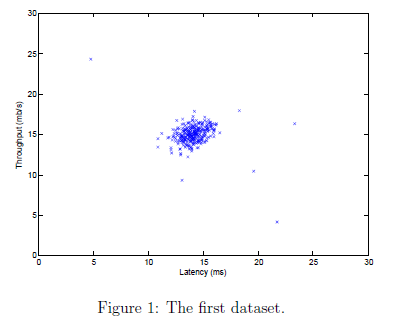

    You will use a Gaussian model to detect anomalous examples in your dataset. You will first start on a 2D dataset that will allow you to visualize what the algorithm is doing. On that dataset you will fit a Gaussian distribution and then find values that have very low probability and hence can be considered anomalies. After that, you will apply the anomaly detection algorithm to a larger dataset with many dimensions. The code below will visualize the dataset as shown in Figure 1.

% The following command loads the dataset. You should now have the variables X, Xval, yval in your environment
load('ex8data1.mat');

% Visualize the example dataset
plot(X(:, 1), X(:, 2), 'bx');
axis([0 30 0 30]);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

### 1.1 Gaussian distribution

To perform anomaly detection, you will first need to fit a model to the data's distribution. Given a training set $\{x^{(1)},\dots,x^{(m)}\}$ (where $x^{(i)}\in\mathbb{R}^n$), you want to estimate the Gaussian distribution for each of the features $x_i$. For each feature $i = 1\ldots n$ you need to find parameters $\mu_i$ and $\sigma^2_i$ that fit the data in the $i$-th dimension $\{x_i^{(1)},\ldots,x^{(m)}_i\}$(the $i$-th dimension of each example).

    The Gaussian distribution is given by


$$p(x;\mu,\sigma^2)=\frac{1}{\sqrt{2\pi\sigma^2}}e^{-\frac{(x-\mu)^2}{2\sigma^2}}$$


where $\mu$ is the mean and $\sigma^2$ controls the variance.

### 1.2 Estimating parameters for a Gaussian

You can estimate the parameters, $(\mu_i,\sigma_i^2)$, of the $i$-th feature by using the following equations. To estimate the mean, you will use:

$\mu_i = \frac{1}{m}\sum_{j=1}^m{x^{(j)}}$,

and for the variance you will use:

$\sigma^2_i = \frac{1}{m}\sum_{j=1}^m{(x^{(j)}-\mu_i)^2}$.

Your task is to complete the code in `estimateGaussian.m`. This function takes as input the data matrix `X` and should output an $n$-dimension vector `mu` that holds the mean of all the $n$ features and another $n$-dimension vector `sigma2` that holds the variances of all the features. You can implement this using a `for `loop over every feature and every training example (though a vectorized implementation might be more efficient; feel free to use a vectorized implementation if you prefer). Note that in MATLAB, the `var` function will (by default) use $\frac{1}{m-1}$, instead of $\frac{1}{m}$ when computing $\sigma^2_i$.

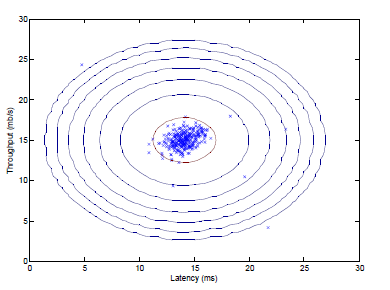

    Once you have completed the code in `estimateGaussian.m`, the code below will visualize the contours of the fitted Gaussian distribution. You should get a plot similar to Figure 2. From your plot, you can see that most of the examples are in the region with the highest probability, while the anomalous examples are in the regions with lower probabilities.

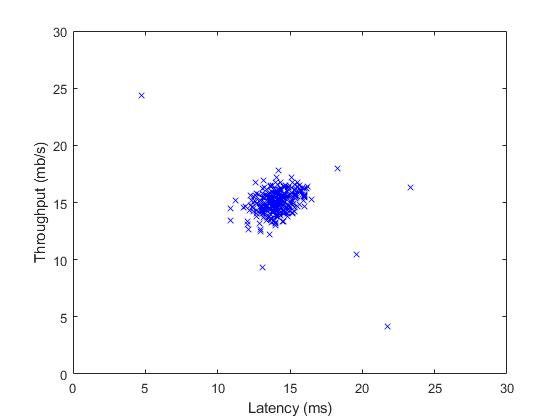

%  Estimate mu and sigma2
[mu, sigma2] = estimateGaussian(X);

%  Returns the density of the multivariate normal at each data point (row) of X
p = multivariateGaussian(X, mu, sigma2);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);

xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.3 Selecting the threshold, $\epsilon$

Now that you have estimated the Gaussian parameters, you can investigate which examples have a very high probability given this distribution and which examples have a very low probability. The low probability examples are more likely to be the anomalies in our dataset. One way to determine which examples are anomalies is to select a threshold based on a cross validation set. In this part of the exercise, you will implement an algorithm to select the threshold $\epsilon$ using the $F_1$ score on a cross validation set.

    You should now complete the code in `selectThreshold.m`. For this, we will use a cross validation set $\{(x^{(1)}_{cv},y^{(1)}_{cv}),\ldots, (x^{(m)}_{cv},y^{(m)}_{cv})\}$, where the label $y = 1$ corresponds to an anomalous example, and $y = 0$ corresponds to a normal example. For each cross validation example, we will compute $p(x^{(i)}_{cv})$. The vector of all of these probabilities $p(x^{(1)}_{cv}),\ldots,p(x^{(m)}_{cv})$ is passed to `selectThreshold.m` in the vector `pval`. The corresponding labels $y^{(1)}_{cv},\ldots,y^{m)}_{cv}$ is passed to the same function in the vector `yval`.

    The function `selectThreshold.m` should return two values; the first is the selected threshold $\epsilon$. If an example $x$ has a low probability $p(x) < \epsilon$, then it is considered to be an anomaly. The function should also return the $F_1$ score, which tells you how well you're doing on finding the ground truth anomalies given a certain threshold. For many different values of $\epsilon$, you will compute the resulting $F_1$ score by computing how many examples the current threshold classifies correctly and incorrectly.

    The $F_1$ score is computed using precision (*prec*) and recall (*rec*):

$F_1 = \frac{2 ( prec)(rec)}{prec + rec}$,

You compute precision and recall by:


$$prec = \frac{tp}{tp + fp}$$



$$rec = \frac{tp}{tp + fn}$$


where

- $tp$ is the number of true positives: the ground truth label says it's an anomaly and our algorithm correctly classified it as an anomaly.

- $fp$ is the number of false positives: the ground truth label says it's not an anomaly, but our algorithm incorrectly classified it as an anomaly.

- $fn$ is the number of false negatives: the ground truth label says it's an anomaly, but our algorithm incorrectly classified it as not being anomalous.

In the provided code `selectThreshold.m`, there is already a loop that will try many different values of $\epsilon$ and select the "best" based $\epsilon$ on the $F_1$ score. You should now complete the code in `selectThreshold.m`. You can implement the computation of the $F_1$ score using a `for` loop over all the cross validation examples (to compute the values $tp,\; fp,\text{and }fn$. You should see a value for epsilon of about `8.99e-05`.

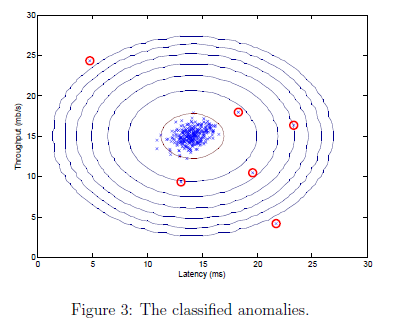

**Implementation Note**: In order to compute $tp,\; fp,\text{and }fn$, you may be able to use a vectorized implementation rather than loop over all the examples. This can be implemented by MATLAB's equality test between a vector and a single number. If you have several binary values in an $n$-dimensional binary vector $v\in\{0,\;1\}^n$, you can find out how many values in this vector are 0 by using: `sum(v == 0)`. You can also apply a logical `and` operator to such binary vectors. For instance, let `cvPredictions` be a binary vector of the size of your cross validation set, where the $i$-th element is 1 if your algorithm considers $x^{(i)}_{cv}$ an anomaly, and 0 otherwise. You can then, for example, compute the number of false positives using:` fp = sum((cvPredictions == 1) & (yval == 0))`.

    Once you have completed the code in `selectThreshold.m`, the code below will detect and circle the anomalies in the plot (Figure 3).

pval = multivariateGaussian(Xval, mu, sigma2);

sigma2 =     1.8326    1.7097


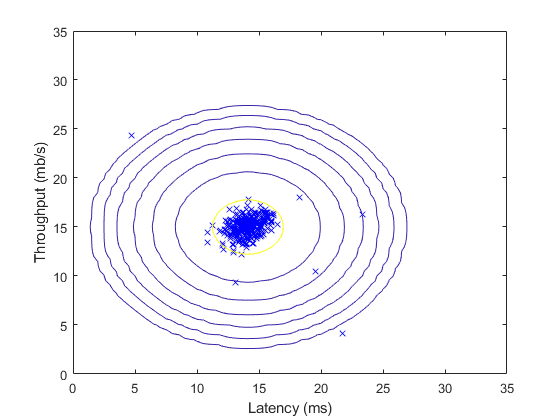


[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);
fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

%  Find the outliers in the training set and plot the
outliers = find(p < epsilon);


%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');
%  Draw a red circle around those outliers
hold on
plot(X(outliers, 1), X(outliers, 2), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
hold off

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.4 High dimensional dataset

The code in this section will run the anomaly detection algorithm you implemented on a more realistic and much harder dataset. In this dataset, each example is described by 11 features, capturing many more properties of your compute servers. The code below will use your code to estimate the Gaussian parameters ($\mu_i$ and $\sigma^2_i$), evaluate the probabilities for both the training data `X` from which you estimated the Gaussian parameters, and do so for the the cross-validation set `Xval`. Finally, it will use `selectThreshold` to find the best threshold $\epsilon$. You should see a value `epsilon` of about `1.38e-18`, and 117 anomalies found.

%  Loads the second dataset. You should now have the variables X, Xval, yval in your environment
load('ex8data2.mat');

%  Apply the same steps to the larger dataset
[mu, sigma2] = estimateGaussian(X);

Best epsilon found using cross-validation: 8.990853e-05


Best F1 on Cross Validation Set:  0.875000


%  Training set 
p = multivariateGaussian(X, mu, sigma2);

%  Cross-validation set
pval = multivariateGaussian(Xval, mu, sigma2);

%  Find the best threshold
[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);
fprintf('Best F1 on Cross Validation Set:  %f\n', F1);
fprintf('# Outliers found: %d\n', sum(p < epsilon));

## 2. Recommender Systems

In this part of the exercise, you will implement the collaborative filtering learning algorithm and apply it to a dataset of movie ratings*. This dataset consists of ratings on a scale of 1 to 5. The dataset has $n_u = 943$ users, and $n_m = 1682$ movies. In the next parts of this exercise, you will implement the function `cofiCostFunc.m` that computes the collaborative fitlering objective function and gradient. After implementing the cost function and gradient, you will use `fmincg.m` to learn the parameters for collaborative filtering.

*[MovieLens 100k Dataset](https://grouplens.org/datasets/movielens/) from GroupLens Research.

### 2.1 Movie ratings dataset

The code in this section will load the dataset `ex8_movies.mat`, providing the variables `Y` and `R` in your MATLAB environment. The matrix `Y` (a `num_movies` $\times$ `num_users` matrix) stores the ratings $y^{(i,j)}$ (from 1 to 5). The matrix `R` is an binary-valued indicator matrix, where` R(i,j) = 1` if user `j` gave a rating to movie `i`, and `R(i,j) = 0` otherwise. The objective of collaborative filtering is to predict movie ratings for the movies that users have not yet rated, that is, the entries with `R(i,j) = 0`. This will allow us to recommend the movies with the highest predicted ratings to the user.

    To help you understand the matrix `Y`, the code below will compute the average movie rating for the first movie (Toy Story) and output the average rating to the screen. Throughout this part of the exercise, you will also be working with the matrices, `X` and `Theta`:

`X = `$\left\lbrack \begin{array}{c}
-{\;\left(x^{\left(1\right)} \right)}^T -\\
-{\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\;\left(x^{\left(n_m \right)} \right)}^T -
\end{array}\right\rbrack$,    `Theta = `$\left\lbrack \begin{array}{c}
-{\;\left(\theta^{\left(1\right)} \right)}^T -\\
-{\;\left(\theta^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\;\left(\theta^{\left(n_u \right)} \right)}^T -
\end{array}\right\rbrack$.

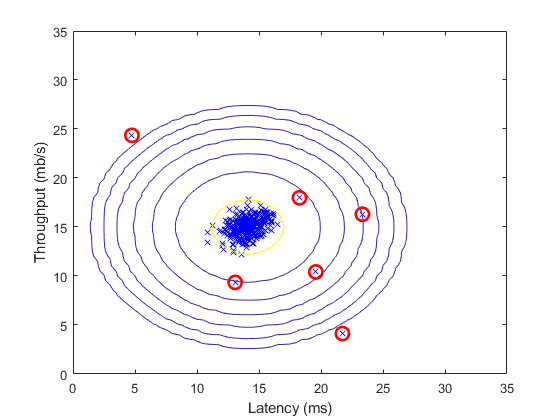

% Load data

load('ex8_movies.mat');

- `Y` is a 1682 x 943 matrix, containing ratings (1 - 5) of 1682 movies on 943 users

- `R` is a 1682 x 943 matrix, where `R(i,j)` = 1 if and only if user `j` gave a rating to movie `i`

% From the matrix, we can compute statistics like average rating.
fprintf('Average rating for movie 1 (Toy Story): %f / 5\n\n', mean(Y(1, R(1, :))));
%  We can "visualize" the ratings matrix by plotting it with imagesc
imagesc(Y);
ylabel('Movies');
xlabel('Users');

The $i$-th row of `X` corresponds to the feature vector $x^{(i)}$ for the $i$-th movie, and the $j$-th row of `Theta` corresponds to one parameter vector $\theta^{(j)}$, for the $j$-th user. Both $x^{(i)}$ and $\theta^{(j)}$ are $n$-dimensional vectors. For the purposes of this exercise, you will use $n = 100$, and therefore, $x^{(i)} \in\mathbb{R}^{100}$ and $\theta^{(j)} \in\mathbb{R}^{100}$. Correspondingly, `X` is a $n_m\times 100$ matrix and `Theta` is a $n_u\times 100$ matrix.

### 2.2 Collaborative filtering learning algorithm

Now, you will start implementing the collaborative filtering learning algorithm. You will start by implementing the cost function (without regularization). The collaborative filtering algorithm in the setting of movie recommendations considers a set of $n$-dimensional parameter vectors $x^{(1)},\ldots,x^{(n_m)}$ and $\theta^{(1)},\ldots, \theta^{(n_u)}$, where the model predicts the rating for movie $i$ by user $j$ as $y^{(i,j)} = (\theta^{(j)})^T x^{(i)}$. Given a dataset that consists of a set of ratings produced by some users on some movies, you wish to learn the parameter vectors $x^{(1)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}$ that produce the best fit (minimizes the squared error).

    You will complete the code in `cofiCostFunc.m` to compute the cost function and gradient for collaborative filtering. Note that the parameters to the function (i.e., the values that you are trying to learn) are `X` and `Theta`. In order to use an off-the-shelf minimizer such as `fmincg`, the cost function has been set up to unroll the parameters into a single vector `params`. You had previously used the same vector unrolling method in the neural networks programming exercise.

#### 2.2.1 Collaborative filtering cost function

The collaborative filtering cost function (without regularization) is given by


$$J\left(x^{(i)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}\right)
=\frac{1}{2}\sum_{(i,j):r(i,j)=1}\left((\theta^{(j)})^Tx^{(i)}-y^{(i,j)}\right)^2$$


You should now modify `cofiCostFunc.m` to return this cost in the variable `J`. Note that you should be accumulating the cost for user $j$ and movie $i$ only if $R(i,j) = 1$. After you have completed the function, the code below will run your cost function. You should expect to see an output of `22.22`.

**Implementation Note:** We strongly encourage you to use a vectorized implementation to compute `J`, since it will later by called many times by the optimization package `fmincg`. As usual, it might be easiest to first write a non-vectorized implementation (to make sure you have the right answer), and the modify it to become a vectorized implementation (checking that the vectorization steps don't change your algorithm's output). To come up with a vectorized implementation, the following tip might be helpful: You can use the `R` matrix to set selected entries to 0. For example, `R.*M` will do an element-wise multiplication between `M` and `R`; since `R` only has elements with values either 0 or 1, this has the effect of setting the elements of `M` to 0 only when the corresponding value in `R` is 0. Hence, `sum(sum(R.*M))` is the sum of all the elements of `M` for which the corresponding element in `R` equals 1.

%  Load pre-trained weights (X, Theta, num_users, num_movies, num_features)
load('ex8_movieParams.mat');

%  Reduce the data set size so that this runs faster
num_users = 4; num_movies = 5; num_features = 3;
X = X(1:num_movies, 1:num_features);
Theta = Theta(1:num_users, 1:num_features);
Y = Y(1:num_movies, 1:num_users);
R = R(1:num_movies, 1:num_users);

Best epsilon found using cross-validation: 1.377229e-18


Best F1 on Cross Validation Set:  0.615385


%  Evaluate cost function

# Outliers found: 117


J = cofiCostFunc([X(:); Theta(:)],  Y, R, num_users, num_movies,num_features, 0);
fprintf('Cost at loaded parameters: %f ',J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.2 Collaborative filtering gradient

Now, you should implement the gradient (without regularization). Specically, you should complete the code in `cofiCostFunc.`m to return the variables `X_grad` and `Theta_gra`d. Note that `X_grad` should be a matrix of the same size as `X` and similarly, `Theta_grad` is a matrix of the same size as `Theta`. The gradients of the cost function is given by:


$$\frac{\partial J}{\partial x_k^{(i)}} 
= \sum_{j:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right)\theta_k^{(j)}$$



$$\frac{\partial J}{\partial \theta_k^{(j)}} = \sum_{i:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right) x_k^{(i)}$$


Note that the function returns the gradient for both sets of variables by unrolling them into a single vector. After you have completed the code to compute the gradients, the code below will run a gradient check (`checkCostFunction`) to numerically check the implementation of your gradients. (This is similar to the numerical check that you used in the neural networks exercise.) If your implementation is correct, you should find that the analytical and numerical gradients match up closely.

**Implementation Note**: You can get full credit for this assignment without using a vectorized implementation, but your code will run much more slowly (a small number of hours), and so we recommend that you try to vectorize your implementation. To get started, you can implement the gradient with a `for` loop over movies (for computing $\frac{\partial J}{\partial x_k^{(i)}$) and a `for` loop over users (for computing $\frac{\partial J}{\partial \theta_k^{(j)}$). When you first implement the gradient, you might start with an unvectorized version, by implementing another inner `for` loop that computes each element in the summation. After you have completed the gradient computation this way, you should try to vectorize your implementation (vectorize the inner `for` loops), so that you're left with only two `for` loops (one for looping over movies to compute $\frac{\partial J}{\partial x_k^{(i)}$ for each movie, and one for looping over users to compute $\frac{\partial J}{\partial \theta_k^{(j)}$ for each user).

    To perform the vectorization, you might find this helpful: You should come up with a way to compute all the derivatives associated with $x^{(i)}_1,x^{(i)}_2,\ldots,x^{(i)}_n$, (i.e., the derivative terms associated with the feature vector $x^{(i)}$) at the same time. Let us define the derivatives for the feature vector of the $i$-th movie as:


$${\left({\mathrm{X}}_{\mathrm{grad}} \left(\mathrm{i},:\right)\right)}^T =\left\lbrack \begin{array}{c}
\frac{\partial J}{\partial x_1^{\left(i\right)} }\\
\frac{\partial J}{\partial x_2^{\left(i\right)} }\\
\vdots \\
\frac{\partial J}{\partial x_n^{\left(i\right)} }
\end{array}\right\rbrack =\sum_{j:r\left(i,j\right)=1} \left({\left(\theta^{\left(j\right)} \right)}^T x^{\left(i\right)} -y^{\left(i,j\right)} \right)\;\theta^{\left(j\right)}$$


To vectorize the above expression, you can start by indexing into `Theta` and `Y` to select only the elements of interest (that is, those with $r(i,j) = 1$). Intuitively, when you consider the features for the $i$-th movie, you only need to be concerned about the users who had given ratings to the movie, and this allows you to remove all the other users from `Theta` and `Y`.

    Concretely, you can set `idx = find(R(i,:)==1)` to be a list of all the users that have rated movie $i$. This will allow you to create the temporary matrices `Theta_temp = Theta(idx,:)` and `Y_temp = Y(i,idx)` that index into `Theta` and `Y` to give you only the set of users which have rated the $i$-th movie. This will allow you to write the derivatives as:

${\mathrm{X}}_{\textrm{grad}} \left(i,:\right)=\left(\mathrm{X}\left(i,:\right)*{\Theta \;}_{\textrm{temp}}^T -{\mathrm{Y}}_{\textrm{temp}} \right)*{\Theta \;}_{\textrm{temp}}$.

(Note: The vectorized computation above returns a row-vector instead.) After you have vectorized the computations of the derivatives with respect to $x^{(i)}$, you should use a similar method to vectorize the derivatives with respect to $\theta^{(j)}$ as well.

%  Check gradients by running checkNNGradients
checkCostFunction;

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.3 Regularized cost function

The cost function for collaborative filtering with regularization is given by


$$J\left(x^{(i)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}\right)
=\\ \qquad\qquad \frac{1}{2}\sum_{(i,j):r(i,j)=1}\left((\theta^{(j)})^Tx^{(i)}-y^{(i,j)}\right)^2
+\left(\frac{\lambda}{2}\sum_{j=1}^{n_u}{\sum_{k=1}^{n}{(\theta_k^{(j)})^2}}\right)
+\left(\frac{\lambda}{2}\sum_{i=1}^{n_m}{\sum_{k=1}^{n}{(x_k^{(i)})^2}}\right)$$


You should now add regularization to your original computations of the cost function, $J$. After you are done, the code below will run your regularized cost function, and you should expect to see a cost of about `31.34`.

%  Evaluate cost function
J = cofiCostFunc([X(:); Theta(:)], Y, R, num_users, num_movies, num_features, 1.5);      

Average rating for movie 1 (Toy Story): 3.878319 / 5



fprintf('Cost at loaded parameters (lambda = 1.5): %f',J);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.4 Regularized gradient

Now that you have implemented the regularized cost function, you should proceed to implement regularization for the gradient. You should add to your implementation in `cofiCostFunc.m` to return the regularized gradient by adding the contributions from the regularization terms. Note that the gradients for the regularized cost function is given by:


$$\frac{\partial J}{\partial x_k^{(i)}} 
= \sum_{j:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right)\theta_k^{(j)}+\lambda x_k^{(i)}$$



$$\frac{\partial J}{\partial \theta_k^{(j)}} = \sum_{i:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right) x_k^{(i)}+\lambda\theta_k^{(j)}$$


This means that you just need to add $\lambda x^{(i)}$ to the `X_grad(i,:)` variable described earlier, and add $\lambda \theta^{(j)}$ to the `Theta_grad(j,:) `variable described earlier. After you have completed the code to compute the gradients, the code below will run another gradient check (`checkCostFunction`) to numerically check the implementation of your gradients.

%  Check gradients by running checkNNGradients
checkCostFunction(1.5);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 2.3 Learning movie recommendations

After you have finished implementing the collaborative ltering cost function and gradient, you can now start training your algorithm to make movie recommendations for yourself. In the code below, you can enter your own movie preferences, so that later when the algorithm runs, you can get your own movie recommendations! We have filled out some values according to our own preferences, but you should change this according to your own tastes. The list of all movies and their number in the dataset can be found listed in the file movie idx.txt.

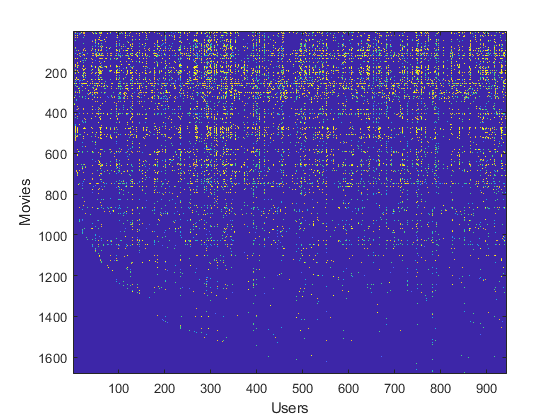

% Load movvie list

movieList = loadMovieList();

% Initialize my ratings
my_ratings = zeros(1682, 1);

% Check the file movie_idx.txt for id of each movie in our dataset
% For example, Toy Story (1995) has ID 1, so to rate it "4", you can set
my_ratings(1) = 4;
% Or suppose did not enjoy Silence of the Lambs (1991), you can set
my_ratings(98) = 2; 

% We have selected a few movies we liked / did not like and the ratings we gave are as follows:
my_ratings(7) = 3;
my_ratings(12)= 5;
my_ratings(54) = 4;
my_ratings(64)= 5;
my_ratings(66)= 3;
my_ratings(69) = 5;
my_ratings(183) = 4;
my_ratings(226) = 5;
my_ratings(355)= 5;

fprintf('\n\nNew user ratings:\n');

ans =      5     3


ans =      4     3


ans =      6     1


X_grad =    -2.5290    7.5757   -1.8998
   -0.5682    3.3527   -0.5234
   -0.8324    4.9116   -0.7668
   -0.3836    2.2633   -0.3533
   -0.8038    4.7427   -0.7404


ans =    -3.7126   -2.9093         0         0
   -1.9906         0         0         0
   -2.9162         0         0         0
   -1.3438         0         0         0
   -2.8159         0         0         0


R = 5×4 logical array
   1   1   0   0
   1   0   0   0
   1   0   0   0
   1   0   0   0
   1   0   0   0


Theta_grad =   -10.5680    4.6278   -7.1600
   -3.0510    1.1644   -3.4741
         0         0         0
         0         0         0


ans =    -3.7126   -1.9906   -2.9162   -1.3438   -2.8159
   -2.9093         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


for i = 1:length(my_ratings)

Cost at loaded parameters: 22.224604 

    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end

#### 2.3.1 Recommendations

After the additional ratings have been added to the dataset, the code below will proceed to train the collaborative filtering model. This will learn the parameters `X` and `Theta`. 

%  Load data
load('ex8_movies.mat');

Array indices must be positive integers or logical values.

Error in cofiCostFunc (line 48)
J = 0.5 * sum(sum((h(R)-Y(R)).^2));  

Error in checkCostFunction>@(t)cofiCostFunc(t,Y,R,num_users,num_movies,num_features,lambda) (line 33)
                @(t) cofiCostFunc(t, Y, R, num_users, num_movies, ...

Error in 


%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies by 943 users
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a rating to movie i
%  Add our own ratings to the data matrix
Y = [my_ratings Y];
R = [(my_ratings ~= 0) R];

%  Normalize Ratings
[Ynorm, Ymean] = normalizeRatings(Y, R);

J = 31.3441

Cost at loaded parameters (lambda = 1.5): 31.344056

%  Useful Values
num_users = size(Y, 2);
num_movies = size(Y, 1);
num_features = 10;

% Set Initial Parameters (Theta, X)
X = randn(num_movies, num_features);
Theta = randn(num_users, num_features);
initial_parameters = [X(:); Theta(:)];

% Set options for fmincg
options = optimset('GradObj','on','MaxIter',100);

% Set Regularization
lambda = 10;
theta = fmincg(@(t)(cofiCostFunc(t, Ynorm, R, num_users, num_movies, num_features,lambda)), initial_parameters, options);

% Unfold the returned theta back into U and W
X = reshape(theta(1:num_movies*num_features), num_movies, num_features);
Theta = reshape(theta(num_movies*num_features+1:end), num_users, num_features);


To predict the rating of movie $i$ for user$j$, you need to compute $(\theta^{(j)})^T x^{(i)}$ The code below computes the ratings for all the movies and users and displays the movies that it recommends (Figure 4), according to ratings that were entered earlier in the script. Note that you might obtain a different set of the predictions due to different random initializations.

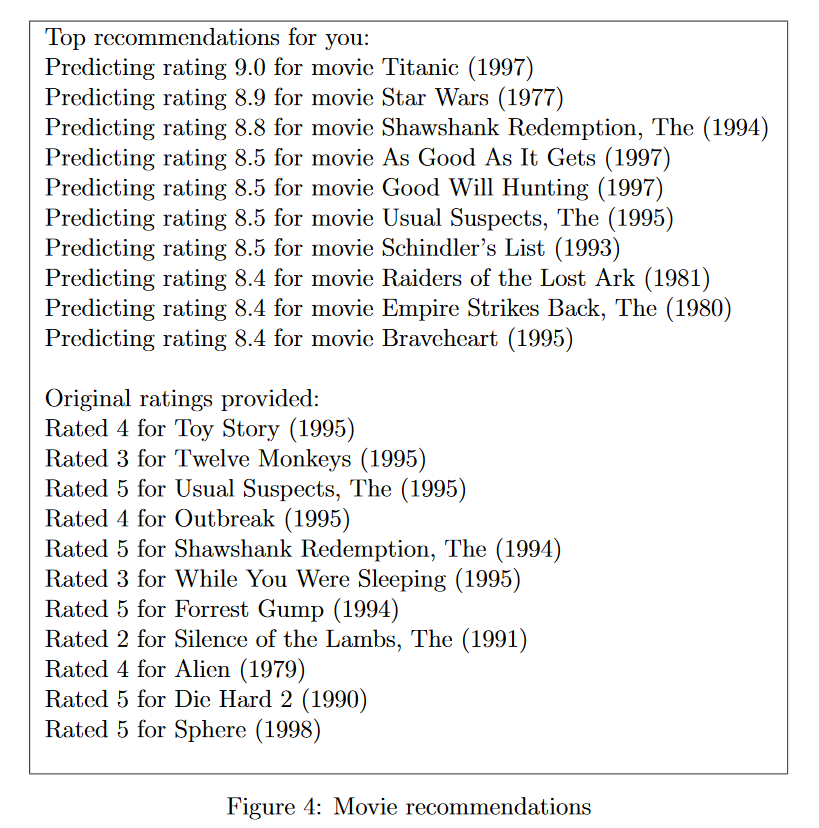

p = X * Theta';
my_predictions = p(:,1) + Ymean;

movieList = loadMovieList();

[r, ix] = sort(my_predictions,'descend');
for i=1:10
    j = ix(i);
    if i == 1
        fprintf('\nTop recommendations for you:\n');
    end
    fprintf('Predicting rating %.1f for movie %s\n', my_predictions(j), movieList{j});
end
for i = 1:length(my_ratings)
    if i == 1
        fprintf('\n\nOriginal ratings provided:\n');



New user ratings:


    end
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)


J = 6.6848e+05

X_grad = 	1.0e+03 *

   -0.0478   -0.3597   -0.4030    1.0084   -0.2190    0.6672   -0.4931    0.2372    1.1474    0.4466
   -0.0535   -0.1259    0.0069   -0.3381    0.0361    0.3026   -0.1011    0.1302   -0.0094   -0.0966
    0.1524    0.0498    0.1157   -0.0624   -0.0645    0.1299    0.0374   -0.0773    0.1403   -0.1643
   -0.1985   -0.0512   -0.2083    0.1996    0.1036   -0.0599    0.0474    0.1184    0.0955   -0.3734
   -0.0896   -0.0739    0.0534   -0.0957   -0.0229    0.0143   -0.2422    0.0029   -0.0176   -0.1002
    0.0143    0.0088    0.0040   -0.0133    0.0134    0.0444    0.0353    0.0393   -0.0300   -0.0332
    0.2418   -0.4807    0.7769    0.1727   -0.8954    0.6499    0.5290   -0.5995    0.1512    0.3679
   -0.2504   -0.1680    0.1664   -0.4543    0.0631   -0.0513    0.0160    0.4738   -0.3534   -0.0121
    0.2142   -0.2425    0.0067    0.4470    0.1915    0.3982    0.3611   -0.3988   -0.0613    0.0275
    0.2460   -0.0767    0.0822   -0.1299   -0.1048   -0.0299   -0.0708

Theta_grad = 	1.0e+03 *

    0.0250    0.0184    0.0009    0.0012    0.0336    0.0309   -0.0151    0.0245   -0.0126    0.0170
    0.2169   -0.3520   -0.0093    0.1458    0.3296    0.0855    0.0836   -0.4003    0.3196   -0.6180
    0.1276   -0.0870    0.0396   -0.1138    0.0430    0.1080   -0.0078    0.1355   -0.0640    0.0543
   -0.0199    0.0538    0.0474    0.0644    0.0847   -0.0400   -0.0306    0.0566   -0.0012   -0.0150
   -0.0260   -0.0393   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0367   -0.0065
   -0.2128    0.0722   -0.1003    0.1999   -0.4132   -0.1718   -0.0155   -0.0919    0.0239    0.1969
    0.0178    0.2792    0.1154   -0.0054   -0.2865   -0.2786   -0.1100   -0.2822    0.2828   -0.0404
    0.1272    0.4912   -0.2851   -0.1339   -0.1928   -0.1077   -0.2571    0.3809    0.2523   -0.3613
   -0.0986    0.0368   -0.0752    0.0662    0.1139    0.0114   -0.0144   -0.1122   -0.0487   -0.1285
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0402    0.

J = 6.6848e+05

X_grad = 	1.0e+03 *

   -0.0478   -0.3597   -0.4030    1.0084   -0.2190    0.6672   -0.4931    0.2372    1.1474    0.4466
   -0.0535   -0.1259    0.0069   -0.3381    0.0361    0.3026   -0.1011    0.1302   -0.0094   -0.0966
    0.1524    0.0498    0.1157   -0.0624   -0.0645    0.1299    0.0374   -0.0773    0.1403   -0.1643
   -0.1985   -0.0512   -0.2083    0.1996    0.1036   -0.0599    0.0474    0.1184    0.0955   -0.3734
   -0.0896   -0.0739    0.0534   -0.0957   -0.0229    0.0143   -0.2422    0.0029   -0.0176   -0.1002
    0.0143    0.0088    0.0040   -0.0133    0.0134    0.0444    0.0353    0.0393   -0.0300   -0.0332
    0.2418   -0.4807    0.7769    0.1727   -0.8954    0.6499    0.5290   -0.5995    0.1512    0.3679
   -0.2504   -0.1680    0.1664   -0.4543    0.0631   -0.0513    0.0160    0.4738   -0.3534   -0.0121
    0.2142   -0.2425    0.0067    0.4470    0.1915    0.3982    0.3611   -0.3988   -0.0613    0.0275
    0.2460   -0.0767    0.0822   -0.1299   -0.1048   -0.0299   -0.0708

Theta_grad = 	1.0e+03 *

    0.0250    0.0184    0.0009    0.0012    0.0336    0.0309   -0.0151    0.0245   -0.0126    0.0170
    0.2169   -0.3520   -0.0093    0.1458    0.3296    0.0855    0.0836   -0.4003    0.3196   -0.6180
    0.1276   -0.0870    0.0396   -0.1138    0.0430    0.1080   -0.0078    0.1355   -0.0640    0.0543
   -0.0199    0.0538    0.0474    0.0644    0.0847   -0.0400   -0.0306    0.0566   -0.0012   -0.0150
   -0.0260   -0.0393   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0367   -0.0065
   -0.2128    0.0722   -0.1003    0.1999   -0.4132   -0.1718   -0.0155   -0.0919    0.0239    0.1969
    0.0178    0.2792    0.1154   -0.0054   -0.2865   -0.2786   -0.1100   -0.2822    0.2828   -0.0404
    0.1272    0.4912   -0.2851   -0.1339   -0.1928   -0.1077   -0.2571    0.3809    0.2523   -0.3613
   -0.0986    0.0368   -0.0752    0.0662    0.1139    0.0114   -0.0144   -0.1122   -0.0487   -0.1285
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0402    0.

J = 6.6848e+05

X_grad = 	1.0e+03 *

   -0.0478   -0.3597   -0.4030    1.0084   -0.2190    0.6672   -0.4931    0.2372    1.1474    0.4466
   -0.0535   -0.1259    0.0069   -0.3381    0.0361    0.3026   -0.1011    0.1302   -0.0094   -0.0966
    0.1524    0.0498    0.1157   -0.0624   -0.0645    0.1299    0.0374   -0.0773    0.1403   -0.1643
   -0.1985   -0.0512   -0.2083    0.1996    0.1036   -0.0599    0.0474    0.1184    0.0955   -0.3734
   -0.0896   -0.0739    0.0534   -0.0957   -0.0229    0.0143   -0.2422    0.0029   -0.0176   -0.1002
    0.0143    0.0088    0.0040   -0.0133    0.0134    0.0444    0.0353    0.0393   -0.0300   -0.0332
    0.2418   -0.4807    0.7769    0.1727   -0.8954    0.6499    0.5290   -0.5995    0.1512    0.3679
   -0.2504   -0.1680    0.1664   -0.4543    0.0631   -0.0513    0.0160    0.4738   -0.3534   -0.0121
    0.2142   -0.2425    0.0067    0.4470    0.1915    0.3982    0.3611   -0.3988   -0.0613    0.0275
    0.2460   -0.0767    0.0822   -0.1299   -0.1048   -0.0299   -0.0708

Theta_grad = 	1.0e+03 *

    0.0250    0.0184    0.0009    0.0012    0.0336    0.0309   -0.0151    0.0245   -0.0126    0.0170
    0.2169   -0.3520   -0.0093    0.1458    0.3296    0.0855    0.0836   -0.4003    0.3196   -0.6180
    0.1276   -0.0870    0.0396   -0.1138    0.0430    0.1080   -0.0078    0.1355   -0.0640    0.0543
   -0.0199    0.0538    0.0474    0.0644    0.0847   -0.0400   -0.0306    0.0566   -0.0012   -0.0150
   -0.0260   -0.0393   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0367   -0.0065
   -0.2128    0.0722   -0.1003    0.1999   -0.4132   -0.1718   -0.0155   -0.0919    0.0239    0.1969
    0.0178    0.2792    0.1154   -0.0054   -0.2865   -0.2786   -0.1100   -0.2822    0.2828   -0.0404
    0.1272    0.4912   -0.2851   -0.1339   -0.1928   -0.1077   -0.2571    0.3809    0.2523   -0.3613
   -0.0986    0.0368   -0.0752    0.0662    0.1139    0.0114   -0.0144   -0.1122   -0.0487   -0.1285
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0402    0.

J = 6.6847e+05

X_grad = 	1.0e+03 *

   -0.0478   -0.3597   -0.4030    1.0084   -0.2190    0.6672   -0.4931    0.2372    1.1474    0.4466
   -0.0535   -0.1259    0.0069   -0.3381    0.0361    0.3026   -0.1011    0.1302   -0.0094   -0.0966
    0.1524    0.0498    0.1157   -0.0624   -0.0645    0.1299    0.0374   -0.0773    0.1403   -0.1643
   -0.1985   -0.0512   -0.2083    0.1995    0.1036   -0.0599    0.0474    0.1184    0.0955   -0.3734
   -0.0896   -0.0739    0.0534   -0.0957   -0.0229    0.0143   -0.2422    0.0029   -0.0176   -0.1002
    0.0143    0.0088    0.0040   -0.0133    0.0134    0.0444    0.0353    0.0393   -0.0300   -0.0332
    0.2418   -0.4807    0.7769    0.1727   -0.8954    0.6499    0.5290   -0.5995    0.1512    0.3679
   -0.2504   -0.1680    0.1664   -0.4543    0.0631   -0.0513    0.0160    0.4738   -0.3534   -0.0121
    0.2142   -0.2425    0.0067    0.4470    0.1915    0.3982    0.3610   -0.3988   -0.0613    0.0275
    0.2460   -0.0767    0.0822   -0.1299   -0.1048   -0.0299   -0.0708

Theta_grad = 	1.0e+03 *

    0.0250    0.0184    0.0009    0.0012    0.0336    0.0309   -0.0151    0.0245   -0.0126    0.0170
    0.2169   -0.3520   -0.0093    0.1458    0.3296    0.0855    0.0836   -0.4002    0.3196   -0.6180
    0.1276   -0.0870    0.0396   -0.1138    0.0430    0.1080   -0.0078    0.1355   -0.0640    0.0543
   -0.0199    0.0538    0.0474    0.0644    0.0847   -0.0400   -0.0306    0.0566   -0.0012   -0.0150
   -0.0260   -0.0393   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0367   -0.0065
   -0.2128    0.0722   -0.1003    0.1999   -0.4132   -0.1718   -0.0155   -0.0919    0.0239    0.1969
    0.0178    0.2792    0.1154   -0.0054   -0.2865   -0.2786   -0.1100   -0.2822    0.2828   -0.0404
    0.1272    0.4912   -0.2851   -0.1339   -0.1928   -0.1077   -0.2571    0.3809    0.2523   -0.3613
   -0.0986    0.0368   -0.0752    0.0662    0.1139    0.0114   -0.0144   -0.1122   -0.0487   -0.1285
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0402    0.

J = 6.6845e+05

X_grad = 	1.0e+03 *

   -0.0478   -0.3596   -0.4030    1.0084   -0.2190    0.6672   -0.4931    0.2372    1.1474    0.4466
   -0.0535   -0.1259    0.0069   -0.3381    0.0361    0.3026   -0.1011    0.1302   -0.0094   -0.0966
    0.1524    0.0498    0.1157   -0.0624   -0.0645    0.1299    0.0374   -0.0773    0.1403   -0.1642
   -0.1985   -0.0512   -0.2083    0.1995    0.1036   -0.0599    0.0474    0.1184    0.0955   -0.3734
   -0.0896   -0.0739    0.0534   -0.0957   -0.0229    0.0143   -0.2422    0.0029   -0.0176   -0.1002
    0.0143    0.0088    0.0040   -0.0133    0.0134    0.0444    0.0353    0.0393   -0.0300   -0.0332
    0.2418   -0.4807    0.7769    0.1727   -0.8954    0.6499    0.5290   -0.5995    0.1512    0.3679
   -0.2504   -0.1680    0.1664   -0.4543    0.0631   -0.0513    0.0160    0.4738   -0.3534   -0.0121
    0.2142   -0.2425    0.0067    0.4470    0.1915    0.3982    0.3610   -0.3988   -0.0613    0.0275
    0.2460   -0.0767    0.0822   -0.1299   -0.1048   -0.0299   -0.0708

Theta_grad = 	1.0e+03 *

    0.0250    0.0184    0.0009    0.0012    0.0336    0.0309   -0.0151    0.0245   -0.0126    0.0170
    0.2169   -0.3520   -0.0093    0.1458    0.3295    0.0855    0.0836   -0.4002    0.3196   -0.6180
    0.1276   -0.0870    0.0396   -0.1138    0.0430    0.1080   -0.0078    0.1355   -0.0640    0.0543
   -0.0199    0.0538    0.0474    0.0644    0.0847   -0.0400   -0.0306    0.0566   -0.0012   -0.0150
   -0.0260   -0.0393   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0367   -0.0065
   -0.2128    0.0722   -0.1003    0.1999   -0.4132   -0.1718   -0.0155   -0.0919    0.0239    0.1969
    0.0178    0.2792    0.1154   -0.0054   -0.2865   -0.2785   -0.1100   -0.2822    0.2828   -0.0404
    0.1272    0.4912   -0.2850   -0.1339   -0.1928   -0.1077   -0.2571    0.3809    0.2523   -0.3613
   -0.0986    0.0368   -0.0752    0.0662    0.1139    0.0114   -0.0144   -0.1122   -0.0487   -0.1284
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0402    0.

J = 6.6840e+05

X_grad = 	1.0e+03 *

   -0.0478   -0.3596   -0.4029    1.0083   -0.2189    0.6671   -0.4931    0.2371    1.1473    0.4465
   -0.0535   -0.1259    0.0069   -0.3381    0.0361    0.3026   -0.1011    0.1302   -0.0094   -0.0966
    0.1524    0.0498    0.1157   -0.0624   -0.0645    0.1299    0.0374   -0.0773    0.1403   -0.1642
   -0.1984   -0.0512   -0.2082    0.1995    0.1036   -0.0599    0.0473    0.1184    0.0955   -0.3734
   -0.0896   -0.0739    0.0534   -0.0956   -0.0229    0.0143   -0.2421    0.0029   -0.0176   -0.1001
    0.0143    0.0088    0.0040   -0.0133    0.0134    0.0444    0.0353    0.0393   -0.0300   -0.0332
    0.2418   -0.4807    0.7768    0.1727   -0.8953    0.6498    0.5290   -0.5994    0.1512    0.3678
   -0.2504   -0.1680    0.1664   -0.4542    0.0631   -0.0513    0.0160    0.4738   -0.3533   -0.0121
    0.2142   -0.2425    0.0067    0.4470    0.1914    0.3981    0.3610   -0.3987   -0.0613    0.0275
    0.2460   -0.0767    0.0822   -0.1299   -0.1048   -0.0299   -0.0708

Theta_grad = 	1.0e+03 *

    0.0250    0.0184    0.0009    0.0012    0.0336    0.0309   -0.0151    0.0245   -0.0126    0.0170
    0.2169   -0.3520   -0.0093    0.1458    0.3295    0.0855    0.0836   -0.4002    0.3196   -0.6179
    0.1276   -0.0869    0.0396   -0.1138    0.0430    0.1080   -0.0078    0.1355   -0.0640    0.0543
   -0.0199    0.0538    0.0474    0.0644    0.0847   -0.0400   -0.0306    0.0566   -0.0012   -0.0150
   -0.0260   -0.0392   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0367   -0.0065
   -0.2128    0.0722   -0.1003    0.1999   -0.4132   -0.1718   -0.0155   -0.0919    0.0239    0.1969
    0.0178    0.2792    0.1154   -0.0054   -0.2865   -0.2785   -0.1100   -0.2822    0.2828   -0.0404
    0.1272    0.4911   -0.2850   -0.1339   -0.1928   -0.1076   -0.2570    0.3808    0.2522   -0.3613
   -0.0986    0.0368   -0.0752    0.0662    0.1138    0.0114   -0.0144   -0.1122   -0.0487   -0.1284
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0402    0.

J = 6.6824e+05

X_grad = 	1.0e+03 *

   -0.0478   -0.3595   -0.4028    1.0080   -0.2189    0.6669   -0.4929    0.2371    1.1469    0.4464
   -0.0535   -0.1259    0.0069   -0.3380    0.0361    0.3025   -0.1011    0.1301   -0.0094   -0.0966
    0.1524    0.0498    0.1157   -0.0624   -0.0645    0.1298    0.0374   -0.0773    0.1403   -0.1642
   -0.1984   -0.0512   -0.2082    0.1995    0.1035   -0.0598    0.0473    0.1184    0.0955   -0.3733
   -0.0896   -0.0739    0.0533   -0.0956   -0.0229    0.0143   -0.2421    0.0029   -0.0176   -0.1001
    0.0143    0.0088    0.0040   -0.0132    0.0134    0.0444    0.0353    0.0393   -0.0300   -0.0332
    0.2417   -0.4805    0.7766    0.1726   -0.8950    0.6496    0.5288   -0.5992    0.1512    0.3677
   -0.2503   -0.1680    0.1664   -0.4541    0.0631   -0.0513    0.0160    0.4736   -0.3532   -0.0121
    0.2141   -0.2425    0.0067    0.4469    0.1914    0.3980    0.3609   -0.3987   -0.0612    0.0275
    0.2459   -0.0767    0.0822   -0.1299   -0.1048   -0.0300   -0.0708

Theta_grad = 	1.0e+03 *

    0.0250    0.0183    0.0009    0.0012    0.0336    0.0309   -0.0151    0.0245   -0.0126    0.0170
    0.2169   -0.3519   -0.0093    0.1457    0.3294    0.0855    0.0836   -0.4001    0.3195   -0.6178
    0.1276   -0.0869    0.0396   -0.1138    0.0430    0.1079   -0.0078    0.1354   -0.0640    0.0543
   -0.0199    0.0538    0.0474    0.0644    0.0847   -0.0400   -0.0306    0.0566   -0.0012   -0.0150
   -0.0260   -0.0392   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0367   -0.0065
   -0.2128    0.0721   -0.1003    0.1998   -0.4131   -0.1717   -0.0155   -0.0919    0.0239    0.1969
    0.0178    0.2791    0.1154   -0.0054   -0.2864   -0.2785   -0.1099   -0.2821    0.2827   -0.0404
    0.1272    0.4910   -0.2849   -0.1338   -0.1927   -0.1076   -0.2570    0.3807    0.2522   -0.3612
   -0.0986    0.0368   -0.0752    0.0662    0.1138    0.0114   -0.0144   -0.1121   -0.0487   -0.1284
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0402    0.

J = 6.6775e+05

X_grad = 	1.0e+03 *

   -0.0476   -0.3592   -0.4023    1.0070   -0.2187    0.6663   -0.4926    0.2369    1.1458    0.4460
   -0.0535   -0.1258    0.0069   -0.3377    0.0360    0.3022   -0.1010    0.1300   -0.0094   -0.0965
    0.1523    0.0498    0.1156   -0.0623   -0.0645    0.1297    0.0374   -0.0773    0.1402   -0.1641
   -0.1982   -0.0512   -0.2080    0.1993    0.1034   -0.0598    0.0473    0.1183    0.0954   -0.3730
   -0.0895   -0.0739    0.0533   -0.0955   -0.0228    0.0143   -0.2419    0.0030   -0.0176   -0.1001
    0.0143    0.0088    0.0040   -0.0132    0.0134    0.0443    0.0352    0.0393   -0.0300   -0.0332
    0.2414   -0.4800    0.7759    0.1725   -0.8942    0.6490    0.5284   -0.5987    0.1511    0.3674
   -0.2502   -0.1679    0.1662   -0.4538    0.0631   -0.0513    0.0159    0.4733   -0.3529   -0.0122
    0.2140   -0.2423    0.0067    0.4466    0.1912    0.3977    0.3607   -0.3984   -0.0612    0.0275
    0.2458   -0.0766    0.0821   -0.1298   -0.1047   -0.0300   -0.0707

Theta_grad = 	1.0e+03 *

    0.0250    0.0183    0.0009    0.0011    0.0336    0.0309   -0.0150    0.0245   -0.0126    0.0170
    0.2167   -0.3517   -0.0093    0.1456    0.3292    0.0854    0.0835   -0.3998    0.3192   -0.6173
    0.1276   -0.0869    0.0396   -0.1137    0.0430    0.1079   -0.0078    0.1354   -0.0639    0.0543
   -0.0199    0.0538    0.0474    0.0644    0.0847   -0.0400   -0.0306    0.0566   -0.0012   -0.0150
   -0.0260   -0.0392   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0367   -0.0065
   -0.2127    0.0721   -0.1002    0.1997   -0.4129   -0.1716   -0.0155   -0.0918    0.0238    0.1967
    0.0178    0.2789    0.1153   -0.0053   -0.2862   -0.2783   -0.1099   -0.2819    0.2826   -0.0404
    0.1271    0.4906   -0.2847   -0.1337   -0.1926   -0.1075   -0.2568    0.3804    0.2519   -0.3609
   -0.0985    0.0367   -0.0752    0.0662    0.1137    0.0114   -0.0144   -0.1121   -0.0487   -0.1284
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0402    0.

J = 6.6630e+05

X_grad = 	1.0e+03 *

   -0.0472   -0.3582   -0.4010    1.0042   -0.2183    0.6645   -0.4915    0.2363    1.1426    0.4449
   -0.0535   -0.1256    0.0069   -0.3370    0.0360    0.3015   -0.1007    0.1297   -0.0093   -0.0963
    0.1520    0.0497    0.1154   -0.0622   -0.0643    0.1295    0.0373   -0.0771    0.1399   -0.1638
   -0.1976   -0.0511   -0.2074    0.1987    0.1030   -0.0597    0.0471    0.1181    0.0951   -0.3721
   -0.0894   -0.0738    0.0532   -0.0953   -0.0228    0.0143   -0.2414    0.0030   -0.0176   -0.0999
    0.0142    0.0088    0.0040   -0.0132    0.0134    0.0443    0.0352    0.0393   -0.0299   -0.0332
    0.2405   -0.4786    0.7737    0.1722   -0.8918    0.6473    0.5272   -0.5972    0.1508    0.3664
   -0.2497   -0.1675    0.1657   -0.4529    0.0631   -0.0513    0.0158    0.4722   -0.3519   -0.0122
    0.2136   -0.2417    0.0068    0.4457    0.1907    0.3968    0.3599   -0.3975   -0.0611    0.0274
    0.2454   -0.0765    0.0820   -0.1295   -0.1045   -0.0300   -0.0706

Theta_grad = 	1.0e+03 *

    0.0250    0.0183    0.0009    0.0011    0.0335    0.0309   -0.0150    0.0245   -0.0125    0.0170
    0.2163   -0.3511   -0.0091    0.1452    0.3284    0.0851    0.0833   -0.3988    0.3185   -0.6160
    0.1274   -0.0868    0.0395   -0.1135    0.0430    0.1077   -0.0078    0.1352   -0.0638    0.0542
   -0.0199    0.0538    0.0473    0.0643    0.0845   -0.0399   -0.0306    0.0565   -0.0012   -0.0150
   -0.0259   -0.0392   -0.0144   -0.0158   -0.0022    0.0106   -0.0057    0.0225   -0.0366   -0.0065
   -0.2124    0.0720   -0.1000    0.1994   -0.4122   -0.1714   -0.0155   -0.0917    0.0238    0.1963
    0.0177    0.2784    0.1151   -0.0053   -0.2857   -0.2778   -0.1097   -0.2814    0.2820   -0.0403
    0.1267    0.4894   -0.2841   -0.1334   -0.1923   -0.1071   -0.2562    0.3794    0.2512   -0.3600
   -0.0983    0.0367   -0.0750    0.0661    0.1135    0.0115   -0.0143   -0.1119   -0.0486   -0.1281
   -0.0101    0.0329   -0.0044    0.0134    0.0054    0.0401    0.

J = 6.6195e+05

X_grad = 	1.0e+03 *

   -0.0460   -0.3552   -0.3971    0.9956   -0.2169    0.6590   -0.4883    0.2345    1.1331    0.4416
   -0.0534   -0.1248    0.0068   -0.3347    0.0358    0.2994   -0.1000    0.1288   -0.0092   -0.0956
    0.1512    0.0493    0.1148   -0.0617   -0.0638    0.1287    0.0373   -0.0765    0.1392   -0.1628
   -0.1960   -0.0510   -0.2057    0.1971    0.1019   -0.0592    0.0467    0.1174    0.0942   -0.3696
   -0.0889   -0.0735    0.0530   -0.0945   -0.0226    0.0142   -0.2399    0.0033   -0.0177   -0.0995
    0.0141    0.0087    0.0040   -0.0131    0.0134    0.0441    0.0351    0.0392   -0.0297   -0.0331
    0.2380   -0.4743    0.7674    0.1712   -0.8846    0.6422    0.5236   -0.5927    0.1500    0.3634
   -0.2482   -0.1665    0.1643   -0.4502    0.0630   -0.0514    0.0153    0.4691   -0.3491   -0.0124
    0.2123   -0.2400    0.0069    0.4430    0.1892    0.3939    0.3577   -0.3950   -0.0608    0.0272
    0.2441   -0.0760    0.0815   -0.1287   -0.1038   -0.0302   -0.0702

Theta_grad = 	1.0e+03 *

    0.0249    0.0182    0.0009    0.0010    0.0334    0.0309   -0.0149    0.0245   -0.0125    0.0169
    0.2152   -0.3492   -0.0088    0.1440    0.3261    0.0843    0.0826   -0.3960    0.3163   -0.6120
    0.1269   -0.0864    0.0392   -0.1129    0.0429    0.1072   -0.0078    0.1346   -0.0635    0.0539
   -0.0197    0.0536    0.0471    0.0639    0.0842   -0.0398   -0.0305    0.0562   -0.0012   -0.0150
   -0.0259   -0.0392   -0.0144   -0.0156   -0.0022    0.0106   -0.0057    0.0225   -0.0365   -0.0065
   -0.2115    0.0717   -0.0994    0.1985   -0.4103   -0.1705   -0.0154   -0.0913    0.0236    0.1952
    0.0175    0.2768    0.1145   -0.0050   -0.2839   -0.2762   -0.1090   -0.2797    0.2804   -0.0402
    0.1258    0.4860   -0.2822   -0.1323   -0.1913   -0.1061   -0.2544    0.3766    0.2491   -0.3575
   -0.0978    0.0365   -0.0746    0.0657    0.1127    0.0116   -0.0142   -0.1114   -0.0485   -0.1275
   -0.0100    0.0328   -0.0044    0.0133    0.0054    0.0400    0.

J = 6.4909e+05

X_grad = 	1.0e+03 *

   -0.0426   -0.3463   -0.3853    0.9703   -0.2128    0.6428   -0.4786    0.2293    1.1048    0.4318
   -0.0534   -0.1225    0.0066   -0.3281    0.0354    0.2930   -0.0978    0.1261   -0.0089   -0.0937
    0.1487    0.0481    0.1129   -0.0604   -0.0624    0.1263    0.0370   -0.0748    0.1370   -0.1599
   -0.1911   -0.0504   -0.2007    0.1924    0.0985   -0.0580    0.0454    0.1152    0.0915   -0.3620
   -0.0875   -0.0727    0.0522   -0.0924   -0.0219    0.0139   -0.2353    0.0040   -0.0178   -0.0981
    0.0138    0.0086    0.0039   -0.0128    0.0133    0.0437    0.0348    0.0389   -0.0292   -0.0329
    0.2305   -0.4615    0.7484    0.1682   -0.8633    0.6269    0.5128   -0.5791    0.1474    0.3546
   -0.2439   -0.1635    0.1601   -0.4422    0.0629   -0.0516    0.0138    0.4598   -0.3405   -0.0130
    0.2086   -0.2350    0.0075    0.4350    0.1847    0.3855    0.3510   -0.3875   -0.0599    0.0266
    0.2403   -0.0746    0.0802   -0.1264   -0.1017   -0.0306   -0.0691

Theta_grad = 	1.0e+03 *

    0.0248    0.0180    0.0009    0.0008    0.0330    0.0308   -0.0147    0.0245   -0.0124    0.0167
    0.2116   -0.3435   -0.0076    0.1404    0.3192    0.0817    0.0806   -0.3877    0.3098   -0.6000
    0.1255   -0.0853    0.0383   -0.1111    0.0427    0.1058   -0.0077    0.1327   -0.0625    0.0531
   -0.0193    0.0531    0.0463    0.0630    0.0831   -0.0393   -0.0303    0.0556   -0.0013   -0.0151
   -0.0257   -0.0390   -0.0143   -0.0153   -0.0022    0.0107   -0.0057    0.0224   -0.0362   -0.0065
   -0.2087    0.0709   -0.0978    0.1959   -0.4044   -0.1681   -0.0151   -0.0900    0.0230    0.1917
    0.0170    0.2722    0.1127   -0.0044   -0.2789   -0.2715   -0.1072   -0.2748    0.2755   -0.0398
    0.1228    0.4756   -0.2764   -0.1292   -0.1884   -0.1029   -0.2491    0.3680    0.2429   -0.3498
   -0.0963    0.0360   -0.0733    0.0648    0.1105    0.0118   -0.0138   -0.1097   -0.0483   -0.1257
   -0.0098    0.0326   -0.0044    0.0132    0.0053    0.0396    0.

J = 6.1203e+05

X_grad = 	1.0e+03 *

   -0.0326   -0.3202   -0.3512    0.8966   -0.2007    0.5956   -0.4503    0.2141    1.0224    0.4030
   -0.0530   -0.1157    0.0060   -0.3088    0.0339    0.2744   -0.0914    0.1182   -0.0079   -0.0880
    0.1415    0.0448    0.1076   -0.0565   -0.0581    0.1193    0.0362   -0.0698    0.1304   -0.1514
   -0.1770   -0.0487   -0.1863    0.1787    0.0888   -0.0543    0.0417    0.1090    0.0837   -0.3399
   -0.0835   -0.0705    0.0499   -0.0860   -0.0201    0.0130   -0.2222    0.0060   -0.0183   -0.0942
    0.0129    0.0082    0.0036   -0.0120    0.0132    0.0424    0.0338    0.0382   -0.0277   -0.0322
    0.2088   -0.4243    0.6935    0.1592   -0.8013    0.5824    0.4812   -0.5396    0.1399    0.3288
   -0.2312   -0.1548    0.1480   -0.4189    0.0624   -0.0522    0.0096    0.4328   -0.3158   -0.0145
    0.1978   -0.2203    0.0090    0.4115    0.1716    0.3608    0.3315   -0.3654   -0.0573    0.0248
    0.2292   -0.0704    0.0765   -0.1195   -0.0957   -0.0317   -0.0658

Theta_grad = 	1.0e+03 *

    0.0244    0.0172    0.0008    0.0001    0.0319    0.0305   -0.0140    0.0245   -0.0122    0.0161
    0.2013   -0.3269   -0.0045    0.1300    0.2991    0.0744    0.0748   -0.3634    0.2907   -0.5650
    0.1212   -0.0822    0.0358   -0.1060    0.0421    0.1016   -0.0075    0.1274   -0.0596    0.0507
   -0.0182    0.0517    0.0442    0.0602    0.0799   -0.0380   -0.0297    0.0536   -0.0016   -0.0151
   -0.0252   -0.0384   -0.0142   -0.0141   -0.0022    0.0108   -0.0057    0.0223   -0.0352   -0.0066
   -0.2007    0.0684   -0.0929    0.1881   -0.3873   -0.1609   -0.0143   -0.0865    0.0214    0.1814
    0.0153    0.2586    0.1073   -0.0024   -0.2640   -0.2578   -0.1019   -0.2604    0.2612   -0.0387
    0.1142    0.4453   -0.2597   -0.1201   -0.1799   -0.0938   -0.2337    0.3429    0.2247   -0.3274
   -0.0918    0.0344   -0.0697    0.0619    0.1039    0.0126   -0.0126   -0.1050   -0.0474   -0.1203
   -0.0092    0.0321   -0.0043    0.0129    0.0050    0.0384    0.

J = 5.1375e+05

X_grad =    -6.3822 -247.0790 -259.2058  695.4838 -166.2552  465.9964 -370.7415  171.9274  798.5350  322.9717
  -51.3212  -97.1510    4.0182 -256.2050   29.8711  223.6810  -74.3892   96.6125   -5.1531  -72.2157
  121.6328   35.4976   92.5493  -45.9202  -46.7026   99.9568   33.7264  -56.3681  112.4318 -127.8214
 -139.5742  -43.6969 -147.5441  142.3948   63.4957  -44.2388   32.2310   91.7575   63.1603 -280.0182
  -71.9810  -63.9087   43.5419  -68.9251  -15.3334   10.5290 -186.3818   11.1500  -19.1519  -82.8860
   10.4443    7.1416    2.8569   -9.9496   12.7428   38.7099   30.9036   35.9329  -23.5347  -30.2021
  151.9126 -323.5354  544.7335  132.6085 -633.5518  460.4975  393.7601 -429.7868  118.1815  258.1259
 -195.6731 -130.9282  115.4300 -354.5715   60.3616  -53.3432   -0.5242  359.0995 -249.0332  -18.1817
  167.8932 -179.9955   12.3747  346.7411  136.7354  292.9053  277.7221 -304.1817  -49.4284   19.5259
  198.5848  -58.8636   66.0021 -100.6789  -79.1025  -34.5864  -56.8058   93.4728  

Theta_grad = 	1.0e+03 *

    0.0232    0.0151    0.0007   -0.0019    0.0290    0.0297   -0.0121    0.0245   -0.0115    0.0143
    0.1725   -0.2805    0.0040    0.1015    0.2437    0.0548    0.0588   -0.2964    0.2387   -0.4685
    0.1093   -0.0733    0.0291   -0.0916    0.0400    0.0898   -0.0070    0.1124   -0.0515    0.0437
   -0.0150    0.0475    0.0383    0.0525    0.0709   -0.0342   -0.0277    0.0481   -0.0024   -0.0152
   -0.0238   -0.0367   -0.0139   -0.0111   -0.0021    0.0112   -0.0056    0.0219   -0.0325   -0.0066
   -0.1781    0.0612   -0.0794    0.1662   -0.3389   -0.1404   -0.0120   -0.0765    0.0172    0.1529
    0.0111    0.2208    0.0922    0.0029   -0.2228   -0.2196   -0.0870   -0.2205    0.2212   -0.0353
    0.0900    0.3609   -0.2136   -0.0940   -0.1557   -0.0689   -0.1906    0.2730    0.1746   -0.2651
   -0.0793    0.0302   -0.0596    0.0540    0.0858    0.0146   -0.0094   -0.0918   -0.0448   -0.1051
   -0.0075    0.0306   -0.0040    0.0121    0.0043    0.0351    0.

J = 3.1497e+05

X_grad =    44.6530  -69.9912  -62.0173  248.9523  -79.0779  172.9847 -174.8402   72.1175  306.6107  135.7792
  -40.1542  -55.8637   -3.2505 -142.3932   19.0673  113.6766  -40.0530   49.5154    0.7836  -35.0501
   75.2608   14.0490   57.1122  -23.6462  -22.2719   56.1324   26.4287  -27.4275   71.7337  -73.5686
  -64.1022  -29.9001  -67.8867   69.6358   16.6172  -22.3192   16.3239   52.0781   22.4223 -149.6794
  -42.8556  -46.6315   27.3851  -33.7292   -6.1114    5.3247 -109.2201   18.9968  -18.2874  -54.2147
    6.5988    3.7186    1.1713   -6.1029   11.2431   29.1862   23.4750   29.5735  -14.7666  -24.6811
   41.1990 -104.6108  221.2158   58.5834 -272.2364  186.2868  190.5017 -171.2824   60.5094   97.3473
 -110.6317  -77.3800   46.5765 -207.9122   50.7996  -50.6093  -14.2751  196.9735 -108.0223  -22.5732
   97.9282  -88.1147   13.9748  196.8202   64.4367  137.9787  154.0212 -159.4583  -26.3956    5.3553
  127.8364  -33.3716   41.5666  -57.8912  -42.5548  -37.9498  -35.7272   60.8501  

Theta_grad =    20.3722   10.1475    0.8606   -6.0558   22.4541   27.2919   -8.0850   24.0782   -9.8386   10.6347
  103.7726 -168.6548   20.7308   37.9784  115.6784   13.9607   21.7362 -143.8286  122.3696 -246.0611
   79.9060  -51.8340   14.9568  -58.5527   32.7318   61.3457   -5.7301   76.8772  -33.0079   25.1980
   -8.0157   36.9157   24.1911   34.7588   49.7061  -25.4785  -21.9910   35.5741   -4.0999  -14.9928
  -20.8063  -32.3551  -12.6160   -4.9953   -1.6356   12.1836   -5.5248   20.9408  -25.8948   -6.4691
 -122.0064   42.2225  -49.3090  112.4154 -219.9697  -87.8791   -6.0958  -52.3325    9.3883   85.2044
    3.2175  131.8342   55.3791   14.1198 -126.5541 -130.1815  -51.6946 -128.0478  125.9200  -26.6852
   30.8547  160.8481 -106.5326  -27.7555  -95.4868  -13.7262  -88.7416  107.0908   61.7113 -117.1935
  -51.2031   20.5631  -37.7429   35.5325   44.5831   18.7734   -2.2288  -59.4855  -36.2520  -68.2618
   -3.7893   26.4098   -2.6257   10.3697    3.4312   27.5005   39.2894   -2.67

Iteration     1 | Cost: 3.149687e+05


J = 1.4237e+05

X_grad =  -116.7895   -7.6236  -95.0566   64.4924   19.4342   29.0312   73.7899    5.3921   77.0306  -14.6397
   16.1434  -23.7301   -2.8383  -48.6121  -10.4624   22.1364  -15.6066   17.9720    2.3512   13.9847
   -2.2951   -2.1204   11.9364   -2.9871  -11.5101    5.8589   11.2523   -1.0990   18.6833   -1.4807
  -11.3355    6.0087  -23.7799   15.8832   18.1705    5.1403    5.5952    1.2362   20.1208  -14.8528
   10.7442    8.6986  -41.5172  -16.0042  -10.9079  -12.3071  -90.5230  -18.3685   37.1831   22.9622
   20.7043   -9.4310   10.5136   -9.4398   -4.1276    2.9668    0.9738    9.4984  -16.3626   -1.1095
   49.8998  -37.1135   20.5547  -22.3250  -16.9976    1.8856  -54.9500   12.1152  -28.0360    4.8803
    4.7849   -7.4308    8.3753  -17.2390  -10.6426    9.2523   27.9022   22.1221  -36.0493   -6.7917
  -33.6155   22.9223  -32.2722  -10.7909    9.7734   -7.8199  -29.5700   36.9895   44.6032  -17.4278
   25.5362   -1.6801    1.8517  -11.1893   -6.0625    5.4788    2.6977   11.8138  

Theta_grad = 	1.0e+03 *

    0.0121    0.0027    0.0087   -0.0064    0.0135    0.0207   -0.0037    0.0152   -0.0033    0.0102
   -0.0063    0.0381    0.0012    0.0028   -0.0040   -0.0014    0.0025    0.0114   -0.0098    0.0270
    0.0048   -0.0007    0.0067   -0.0070    0.0051    0.0140    0.0035    0.0182   -0.0067   -0.0012
   -0.0092    0.0097    0.0024    0.0088    0.0179   -0.0059   -0.0012    0.0081   -0.0084    0.0014
   -0.0071   -0.0158   -0.0004   -0.0049   -0.0042    0.0111   -0.0042    0.0065   -0.0110   -0.0002
    0.0076   -0.0063   -0.0174   -0.0097    0.0284    0.0312    0.0066    0.0113    0.0091   -0.0177
    0.0073   -0.0038   -0.0085    0.0039    0.0144   -0.0049    0.0103    0.0020   -0.0293    0.0044
    0.0104   -0.0277    0.0199    0.0029    0.0314   -0.0255    0.0144   -0.0058    0.0183    0.0237
   -0.0163    0.0084   -0.0122    0.0098    0.0081    0.0029    0.0014   -0.0091   -0.0032   -0.0164
    0.0016    0.0129    0.0048    0.0024    0.0046    0.0114    0.

Iteration     2 | Cost: 1.423683e+05


J = 6.2759e+05

X_grad = 	1.0e+03 *

    1.1198   -0.6243    0.8837   -0.9317   -0.6469   -0.2867   -0.3095    0.2033   -1.1941    0.5291
    0.0286    0.0830   -0.2176   -0.0582    0.0107    0.0349   -0.2374   -0.0339    0.2184    0.0402
   -0.0032    0.0008   -0.0016   -0.0109   -0.0075    0.0093    0.0052    0.0004    0.0034   -0.0016
    0.3584   -0.1588    0.1865   -0.2785   -0.2088   -0.1161   -0.2331    0.0198   -0.2767    0.2180
   -0.3607   -0.5515    1.3024    0.2736    0.0916    0.1856    2.0840    0.4630   -1.3419   -0.4820
    0.0151   -0.0060    0.0071   -0.0095   -0.0128    0.0029   -0.0104    0.0040   -0.0207    0.0030
   -0.3653    0.2293   -0.3016    0.2797    0.2560    0.0685    0.1108   -0.0623    0.3761   -0.1943
    0.1265    0.3741   -0.8239   -0.0642   -0.0020   -0.0778   -1.1601   -0.3025    0.8586    0.2260
    0.4010   -0.2322    0.3108   -0.3625   -0.2641   -0.1053   -0.1048    0.0896   -0.4301    0.2044
    0.0075    0.0041   -0.0084   -0.0054   -0.0006    0.0132    0.0069

Theta_grad = 	1.0e+04 *

    0.0005    0.0003    0.0010   -0.0002    0.0012    0.0014   -0.0000    0.0006   -0.0000    0.0008
   -0.0017    0.0020   -0.0006    0.0009   -0.0008    0.0009    0.0008    0.0012   -0.0004    0.0019
   -0.0006    0.0005    0.0002   -0.0001    0.0000    0.0009    0.0003    0.0002   -0.0002   -0.0002
   -0.0005    0.0006   -0.0001    0.0005    0.0013    0.0003    0.0004   -0.0002   -0.0001    0.0006
   -0.0003   -0.0005   -0.0001   -0.0002   -0.0001    0.0007    0.0000   -0.0001   -0.0005   -0.0000
    0.0026   -0.0006    0.0002   -0.0017    0.0024    0.0003   -0.0025   -0.0006   -0.0001    0.0002
   -0.0000   -0.0017    0.0002    0.0001    0.0008    0.0012    0.0024    0.0004   -0.0026    0.0006
   -0.0017   -0.0007    0.0035    0.0002   -0.0001    0.0018    0.0062   -0.0002   -0.0022   -0.0021
   -0.0012    0.0006   -0.0007    0.0006    0.0004    0.0003   -0.0003    0.0002    0.0006   -0.0005
    0.0005    0.0006    0.0008    0.0003    0.0005    0.0005    0.

J = 1.0329e+05

X_grad =   -16.6483  -13.7514  -12.1171   -3.2616    2.1197   -0.7382   24.6692    2.0066  -10.8883   -4.3336
   13.7949   -7.9778  -18.2401  -32.2897   -5.8399   10.8914  -37.9967    7.9084   22.1514   13.0366
   -4.9216   -0.3424    8.6307   -2.3447   -9.9095    4.9295    8.3379    0.0056   13.3519   -0.3357
    6.3321   -2.2734   -2.1300    2.9360    5.0055   -1.9896    5.2897    2.1402   -3.5693   -2.0612
   10.0357   -0.8962  -12.7985  -15.7610  -14.1776   -3.8132  -27.7609    1.2484    2.8242    5.6614
    7.5913   -4.1849    1.3407   -2.2512    0.3054    5.8880    1.0389    7.0400   -5.5341   -5.5488
   14.8110  -12.6954   -4.0496  -14.1597    3.8955   -1.0053  -26.4985   13.2797   -9.8655   -3.3470
    6.0557   -0.2143   -6.6054   -5.3512   -6.6789    4.3803    1.9632    5.6055  -12.7349   -0.3638
   -6.6370    9.7772   -8.5864  -24.4990   -5.6619  -13.0556  -22.0081   24.1598   11.2495   -5.9066
   15.5526    1.4740    0.7014   -5.6041   -5.3368    5.5364    2.1239    8.2601  

Theta_grad =     9.1930    2.6325    8.4205   -4.3778   13.2021   18.8597   -2.4735   12.6309   -1.5974    9.5253
   -7.1095   29.8194    1.4512    0.7215   -7.2447    0.8704    2.1330   12.4897  -10.0007   24.6877
    0.5433    1.7912    3.7968   -3.8533    3.6596   11.0887    3.0084   12.0291   -4.0159   -1.4835
   -6.0303    7.4422    3.0271    4.4986   14.2722   -2.6067   -0.0121    3.4565   -8.7045    2.8688
   -6.0766  -12.0017   -1.5454   -1.9834   -2.4491    9.0097   -2.3259    5.5864   -6.4574    0.1890
   10.9375   -7.4988   -5.1394  -11.0320   27.0220   22.0164    5.5906    7.9779    1.4414  -13.2022
    3.1292   -5.4068   -9.7959    3.9675   13.2172    1.0744    9.8398    1.5079  -22.0733    6.0736
    2.5656  -16.3245   11.2866    0.2053   19.7665  -11.7110   11.5572   -6.8159   13.6369   14.5535
  -11.6242    6.7127   -6.2980    5.0097    3.6092    3.0248    0.1843   -5.0981   -3.7648  -11.2900
    3.4191   10.1867    3.6671    2.5437    4.8604    9.9834   19.6633   -0.50

Iteration     3 | Cost: 1.032945e+05


J = 9.4942e+04

X_grad =    72.3228   30.3084   58.3420    2.6001   -5.2044  -28.8925  -32.8602  -22.8252  -20.8471    6.9287
  -63.6824   15.5505   17.9205   55.1165   32.1826  -22.7805   36.4625  -23.0577   -2.5930    2.6168
   13.7454    0.8044   -7.5886   -3.8638   -1.7345    4.5054    4.3842   -4.6373   -1.9114   -9.7806
  -11.2340   17.2552   12.1550   14.6459    4.8083  -21.1164    7.3882  -17.3595   -0.5806   11.7132
  -50.8430   19.6380   33.0675   65.4538   31.3868  -28.0894   35.3652  -27.3824  -14.5674   17.7920
   -4.1941    4.2870   -6.7513    3.4041   -8.6748    9.6430   -9.9508    3.4189  -10.7752   -4.6365
  -37.4669   50.6108   22.4855   37.3997    6.9908  -35.2142   60.4044  -25.3604   26.2376    8.5414
  -35.1190   14.0126   12.4141   56.5740   34.9972  -37.5193    4.5614  -45.8583   16.2456   11.2692
   22.7622   -0.2221   25.6931   26.3139   -1.5077   -8.9438   35.4731  -40.0662  -20.7022   12.9525
   -1.9319    2.7597   -4.7294    2.0756   -5.2083    1.5272    6.2309  -12.5539  

Theta_grad = 	1.0e+03 *

    0.0032    0.0003    0.0056    0.0002    0.0064    0.0085    0.0008    0.0028    0.0007    0.0045
   -0.0059   -0.0260   -0.0043    0.0103    0.0028    0.0057    0.0018   -0.0012    0.0053   -0.0164
   -0.0031    0.0002    0.0032   -0.0071    0.0053    0.0056    0.0013   -0.0023    0.0006   -0.0025
    0.0017    0.0034   -0.0057    0.0043    0.0031    0.0065    0.0018   -0.0030    0.0083    0.0044
   -0.0003    0.0012   -0.0012   -0.0007   -0.0024    0.0013    0.0038   -0.0053   -0.0064    0.0019
    0.0217    0.0141   -0.0202   -0.0117   -0.0156   -0.0175   -0.0710   -0.0256    0.0232    0.0264
   -0.0065   -0.0105    0.0054   -0.0037   -0.0025    0.0111   -0.0034   -0.0031    0.0087    0.0026
   -0.0097    0.0150    0.0101   -0.0115   -0.0348    0.0223    0.0260    0.0081   -0.0269   -0.0334
   -0.0041    0.0032   -0.0003    0.0005    0.0003    0.0009   -0.0024    0.0003    0.0013   -0.0030
    0.0041    0.0042    0.0015    0.0031    0.0013   -0.0001    0.

J = 8.0257e+04

X_grad =    38.4247   13.5897   30.4966  -11.4125    1.7091  -16.6374  -22.4186  -10.3686  -19.6541    0.5262
    9.0378   -7.7480   -0.6172  -24.3267  -11.3865   19.5829   17.5802   17.4429    3.0781  -15.1975
    1.0201   -0.6296    1.7169   -2.0268   -6.3403    3.0323    4.3610   -0.7935    5.1329   -2.9349
   -0.0064    9.5684    0.9277    5.2215    2.3795   -9.5110    2.2402   -6.7222    0.9207    4.7381
    8.0806   -1.0306    9.0866   -7.1442  -10.8838    4.5245   13.0119    8.3948   -9.8758   -4.4168
    0.5225    0.3247   -3.6255    1.4772   -2.8195    6.6233   -3.2998    4.3670   -5.1813   -4.8191
  -17.0462   15.2533    0.7193    3.2389    1.6166   -4.0229   22.0351   -3.8122   12.5338   -0.9978
    3.4599    4.0386   -3.9194    3.5794   -0.9388   -5.2576   -1.3124   -7.4867    4.7720    0.4214
   11.1987   -1.4844   10.4471    0.1972   -7.0787   -4.7900   10.8033  -13.3237   -8.2111    2.0470
    4.9986    2.1618   -1.6693   -1.0030   -5.3981    3.0780    2.8118   -2.0807  

Theta_grad =     5.5517    1.3058    6.7231   -1.5384    9.6005   13.3487   -0.4708    6.9496   -0.1571    6.6971
   -0.9862   -5.5999   -2.8761    0.5428   -3.6920    2.0830   -4.1029    2.7847   -1.0350   -0.1456
   -1.2359    1.2168    2.7149   -4.5463    3.4391    6.5234    2.8081    3.4893   -1.3859   -2.7499
   -1.7051    4.7799   -1.4021    2.3914    7.2417    2.1325    1.7735   -0.3326   -0.6490    3.3358
   -2.4601   -4.7069   -1.0322   -0.0989   -2.1339    4.0168    1.2573    0.9097   -5.1453    0.5477
    6.1791    1.2825    1.8043   -1.1900    3.9648   -3.9296  -16.8037  -10.4930    4.4882    6.7488
   -5.7456   -5.3776    0.6461    2.0241    1.4298    6.5593    4.9406   -2.2850   -3.7381    3.8317
   -1.8824    7.8066   -2.3103   -7.6595  -15.2794    6.6667    6.7882    4.1089   -0.9028  -12.1181
   -6.6641    4.2808   -3.1792    1.9795    1.3315    2.2966   -1.9452   -1.5087   -0.2258   -5.7380
    4.5092    6.1729    2.6758    2.0253    3.0176    4.6581   15.1881    2.51

Iteration     4 | Cost: 8.025731e+04


J = 7.9361e+04

X_grad =    21.7313    6.0178    8.9384   -3.8545  -14.5516   -6.7542  -16.5201    1.1431   11.0996   -1.1270
    7.7802    5.4747    9.9298   -2.6596  -22.0455   12.6699   36.3993   20.2020   -2.1030  -20.6714
    6.2774    2.9052   -3.8856   -0.3416   -6.3678   -2.9191   -1.0646    1.5499    2.2745   -2.7408
   -6.9951    6.3408   -3.5254   -1.2941    1.5239  -13.8140  -12.6920  -14.6138    7.4808    7.5223
   -1.4038   -0.2925    5.7084    2.2581   -5.4114    8.6932   18.3331    8.7356   -0.8911   -9.5639
   -0.5175    3.6145   -2.6140    4.4299   -3.5123    2.2474   -3.3935    1.4006   -3.4813   -1.1935
  -13.0656    8.8345    3.4247    3.6175   -9.1196   -8.9764   12.4418   -5.0059   18.6090   -1.8416
  -11.5744    7.7331   -3.8643   13.9085   12.4840  -24.7560  -25.0704  -27.1936   19.2094   11.9109
   11.8257   -9.4311    7.9530   12.6422   -4.3679    3.5843   11.0640  -16.3932   -5.2455    0.9956
   -2.3539    0.6962   -1.9302    3.0926   -3.6694   -1.9761    1.9795   -6.9209  

Theta_grad = 	1.0e+03 *

    0.0019    0.0001    0.0041    0.0004    0.0048    0.0069    0.0013    0.0017    0.0010    0.0034
   -0.0093   -0.0119    0.0017    0.0162    0.0079   -0.0029    0.0018   -0.0077    0.0022   -0.0071
   -0.0018    0.0001    0.0004   -0.0030    0.0046   -0.0001    0.0011   -0.0002    0.0014   -0.0016
    0.0025    0.0006   -0.0038    0.0002   -0.0009    0.0049   -0.0004   -0.0033    0.0029    0.0027
    0.0003    0.0017   -0.0006    0.0001   -0.0016   -0.0002    0.0035   -0.0039   -0.0022    0.0015
    0.0108    0.0047   -0.0066   -0.0086   -0.0125   -0.0027   -0.0302   -0.0095    0.0083    0.0119
   -0.0017   -0.0074   -0.0003   -0.0029   -0.0017    0.0067   -0.0062   -0.0021    0.0061    0.0007
   -0.0092    0.0150    0.0006    0.0128   -0.0144   -0.0057    0.0097   -0.0038   -0.0034   -0.0119
   -0.0022    0.0043    0.0022    0.0017    0.0003   -0.0022   -0.0007   -0.0004    0.0015   -0.0004
    0.0021    0.0024    0.0019    0.0010    0.0010    0.0007    0.

J = 6.5892e+04

X_grad =    26.5256    8.1453   15.0452   -7.3323   -6.9846   -9.5817  -18.6517   -2.4606   -0.6633   -0.9527
   -3.1923    3.6168    3.1311   -0.8857   -8.2082    6.3531   19.2845   11.5469    5.2505  -11.1724
    3.5649    1.3143   -1.3377   -1.1306   -6.4424   -0.1975    1.4908    0.4873    3.7194   -3.0161
    3.5307    6.1510    0.0990   -4.3509   -4.2461   -6.0059    1.3471   -4.4148    2.3655    1.0950
   -3.8234    1.3714    4.6670    3.2712   -2.6741    1.2722    8.8232    3.5055   -1.9778   -3.1316
    0.3571    2.2440   -2.6484    3.2093   -3.2864    3.7498   -3.1352    2.5136   -4.5160   -2.6849
  -14.2676   11.7075    2.0370    2.6160   -4.7846   -5.4699   15.9310   -3.8742   16.0107   -2.3877
    4.9894    3.3887   -0.6859    1.5009   -2.8986   -6.1527   -1.4378   -6.2684    8.9913   -1.1214
   11.6837   -5.5565    8.8642    6.5820   -6.1175   -0.2195   11.0618  -14.3551   -5.6797    0.5238
    1.1773    1.5111   -1.6558    1.0553   -4.5637    0.4751    2.1441   -4.5362  

Theta_grad =     3.6678    0.6081    5.4291   -0.5110    7.0880    9.9768    0.4703    4.0570    0.4141    4.9410
   -3.4079   -9.2477   -0.4678    7.0253    1.5613   -0.5172   -2.0562   -3.0369    1.0424   -4.3298
   -1.6128    0.6494    1.7347   -3.8235    3.9856    3.0697    2.0410    1.5998    0.0106   -2.2088
    0.5277    2.5036   -2.5988    0.9140    2.8608    3.6883    0.9421   -1.9336    0.9562    2.7591
   -0.9337   -1.1686   -0.6594    0.1432   -1.8359    1.6795    2.5176   -1.6011   -3.4719    1.0411
    8.0374    3.3432   -2.4935   -4.2571   -4.8895   -4.2955  -24.7553  -10.7811    7.0463   10.1838
   -5.7741   -6.3852    1.5482    0.8426   -0.0649    6.5185    0.4975   -2.5838    0.8848    1.8395
   -6.2243   11.4569   -0.6471    4.4729  -13.9538   -0.7320    9.4888   -0.5175   -2.6340  -12.2756
   -4.1876    4.2013   -0.3148    1.7622    0.6220    0.0787   -1.1681   -0.8184    0.6251   -3.0196
    3.1246    4.1918    2.3264    1.5483    2.0248    2.5111   11.6546    2.34

Iteration     5 | Cost: 6.589190e+04


J = 1.0418e+05

X_grad =     1.8168    4.9421   -4.6071    1.7018  -13.3328   -8.2484   -6.5583    3.4731   15.8505    0.5243
 -122.3991  -49.7292  113.7177   96.1960   69.3474    4.6647  163.4045    4.7818  -98.2265  -10.6804
    1.4431    5.7624   -2.9752   -0.6569   -7.1660   -6.9005   -3.0081    3.6682    5.1199    0.0441
   -4.0785   -6.6627    4.7445    1.3444   -2.3793   -0.0411    4.7114   -2.1547   -0.7804   -2.3932
 -120.1263  -50.4963  106.6541   88.5717   69.1030    9.8060  158.7223    7.4487  -91.8580  -13.3074
    0.0137    1.8067   -0.4962    3.1309   -0.7827   -0.4670   -0.1712    1.4497    0.4901   -0.5099
    1.1019   -0.9029   -0.0919    0.5180  -10.0399   -4.9948   -7.1884   -2.7898    9.1422   -1.7753
  -11.0617   -2.4218   13.6132   11.5428    2.6095   -3.5502   13.8852    2.0518   -2.3585   -1.0699
    6.0759   -6.3103    1.3903    6.8596   -3.9267    1.4549   -4.4842   -6.1437    2.4398   -5.1170
   -1.7340   -1.5968   -0.6814    2.9720   -0.1015   -2.8728   -1.1680   -2.7199  

Theta_grad = 	1.0e+03 *

    0.0014    0.0001    0.0033    0.0002    0.0036    0.0054    0.0012    0.0007    0.0008    0.0026
   -0.0021   -0.0005    0.0022    0.0111    0.0012   -0.0016    0.0018   -0.0043    0.0007   -0.0027
   -0.0011   -0.0003   -0.0007    0.0003    0.0029   -0.0022    0.0009    0.0013    0.0012   -0.0014
    0.0001   -0.0011   -0.0030   -0.0003   -0.0009    0.0023   -0.0019   -0.0031   -0.0020    0.0029
    0.0004    0.0015    0.0010   -0.0017   -0.0020    0.0001    0.0023   -0.0033    0.0005    0.0010
   -0.0031   -0.0029    0.0054    0.0013   -0.0015    0.0038    0.0017   -0.0018   -0.0061    0.0038
    0.0023   -0.0034   -0.0027    0.0007   -0.0003    0.0027   -0.0049   -0.0026    0.0018   -0.0008
    0.0070    0.0074   -0.0056    0.0075   -0.0137   -0.0090   -0.0006   -0.0002    0.0126   -0.0032
    0.0000    0.0046    0.0023    0.0011   -0.0014   -0.0020    0.0012    0.0007    0.0022    0.0005
    0.0014    0.0019    0.0023   -0.0006   -0.0005    0.0010    0.

J = 6.1188e+04

X_grad =    18.4537    7.7373    8.2913   -4.7607   -9.3894   -9.2742  -13.7018   -0.3041    5.2154   -0.7008
   -4.1274    6.4097    1.4364    0.7026   -4.4762   -2.5254    8.1179    2.9431    5.0230   -5.8491
    2.9610    2.6828   -1.6597   -0.9435   -6.9759   -2.1253    0.2578    1.5345    4.3155   -2.2334
    1.8780    3.7153    1.3305   -2.8817   -4.6218   -4.6728    3.1951   -2.9417    2.0316   -0.1338
   -9.8931    0.6756    6.7986    6.2986    3.0915   -2.6022    8.7711   -1.0716   -4.0379   -1.4281
    0.2710    1.9832   -2.2467    3.1373   -2.6271    2.5857   -2.4686    2.2935   -2.9602   -2.1631
   -8.8713    8.9465    1.3047    1.3408   -7.2564   -5.6916    8.2538   -2.9976   14.5958   -2.5728
    3.7095    3.5144    0.6898    2.0803   -3.8236   -5.7414   -0.2117   -3.3883    8.2917   -1.3198
   10.0820   -5.0845    6.7959    6.7470   -5.6200    0.0160    6.8613  -11.5898   -2.7910   -1.0718
    0.3825    0.9683   -1.3278    1.5607   -3.6711   -0.5445    1.1145   -3.9483  

Theta_grad =     3.0682    0.4900    4.8869   -0.3155    6.2548    8.8532    0.6642    3.2082    0.5158    4.3854
   -2.9488   -6.7891    0.5558    7.6950    1.5600   -0.8907   -1.0756   -3.5013    0.9693   -3.6924
   -1.4047    0.4074    1.0168   -2.8341    3.6804    1.6789    1.7776    1.5340    0.3564   -1.9087
    0.4787    1.5942   -2.5852    0.4453    1.8538    3.3936    0.2775   -2.3639    0.1261    2.6996
   -0.5523   -0.4996   -0.3121   -0.1232   -1.8238    1.1592    2.4924   -1.8537   -2.2826    1.0052
    4.9125    1.6282   -0.4334   -2.7596   -3.7285   -1.5672  -17.4485   -7.7828    3.7348    8.1944
   -4.3804   -5.8098    0.4459    0.9249    0.3203    5.6411   -1.2411   -2.8960    0.8197    1.3306
   -1.8119   10.6368   -2.2259    4.9744  -14.2700   -3.8534    6.7983   -0.2046    2.7314   -9.6187
   -3.0928    4.2671    0.3644    1.5721    0.1004   -0.4749   -0.5771   -0.4877    1.0179   -2.1742
    2.7126    3.6047    2.3501    0.9493    1.4112    2.1961    9.9960    2.08

Iteration     6 | Cost: 6.118779e+04


J = 5.4163e+04

X_grad =     7.0694    7.1918    0.3919   -0.3996  -11.0214   -9.5196   -5.8512    2.0841   10.0828   -0.2669
   -4.0350    4.4849    2.4436    3.1941   -2.1162   -3.7341    5.2679    2.5931    2.5622   -2.4769
    1.2048    5.1728   -1.4469   -0.9765   -7.8213   -5.2457   -0.9004    3.1917    5.5618   -0.9877
    1.6004   -0.3920    0.5881   -0.4078   -4.3744   -3.0466   -1.1470   -3.2635    3.3509    0.2511
   -6.5607    2.5127    1.9139    2.8158    0.2928   -1.0773    3.7749    2.5078    2.3376   -1.4945
    0.1799    1.3730   -1.2117    2.6314   -1.4286    0.7313   -1.1101    2.0995   -0.2978   -1.5431
   -0.8839    2.8821    1.0906    0.3732   -9.3043   -4.4853   -1.3877   -1.6495    9.2073   -2.7350
    0.8275    3.5036    2.4576    3.6866   -3.6268   -5.4287   -0.3962   -0.1330    5.6331    0.1441
    6.9672   -4.2847    4.0588    6.0494   -4.6757   -0.4402    0.0749   -6.5974    0.8435   -4.2264
   -0.3538   -0.3630   -0.6129    2.0438   -1.7827   -1.8206   -0.7626   -2.1971  

Theta_grad =     2.1891    0.3425    3.9754   -0.1415    4.9406    7.0703    0.7883    1.9355    0.4324    3.5102
    0.4728   -0.8688    0.7178    6.5248   -1.2938   -0.8773   -1.1767   -2.8814    1.1886   -2.0733
   -1.0775   -0.0382    0.0198   -0.8531    2.8629   -0.1795    1.2904    1.6774    0.6059   -1.5493
   -0.5174    0.0015   -2.2987    0.0914    1.1103    2.5023   -0.6850   -2.7639   -2.4564    2.8195
   -0.0301    0.2593    0.4391   -1.1177   -2.0468    0.5080    1.7778   -2.0140   -0.0588    0.8965
   -1.8641   -2.1617    3.7606    1.1843    1.0231    2.2882   -3.8819   -4.3933   -3.2800    5.0032
   -1.1583   -4.1567   -1.2061    1.9469    0.7283    3.9084   -2.2004   -3.3430   -0.3476    0.1801
    6.3995    6.8561   -4.9346    3.2561  -13.8543   -6.3857    1.4387    1.1005   10.7421   -4.9913
   -1.3430    4.3157    0.9714    1.0544   -0.8722   -1.0481    0.2704    0.0407    1.6032   -0.9007
    2.3571    3.0485    2.1406   -0.1188   -0.0252    1.6693    6.9236    1.77

J = 4.9926e+04

X_grad =   -20.4982  -14.6121   -3.5453   12.5127    7.7087    8.6413   11.4994    0.0915   -7.4191    5.2865
   -9.1856  -14.6110    9.9744   12.7040   14.9566    6.3121    5.9841   -3.1093  -13.2959    8.2295
   -2.3255    5.7837   -1.4954   -0.7573   -3.5167   -5.9801   -1.6904    3.0651    2.7497    1.8137
   -4.2106  -24.0039    0.3448    6.6954    6.3189   13.9448  -16.1605   -7.1145   -0.4815    6.7589
   -3.8874    5.3534   -4.1468   -1.0302   -1.7190   -0.4516   -0.2225    6.3458    9.5197   -2.1341
    0.1392    0.8026    1.0405    1.7825    0.7718   -2.3901    1.7365    1.6103    3.7825   -0.4064
    2.3726  -28.6694    3.1021    4.0823    6.9440   13.6970  -14.6155  -10.1790  -18.4131    3.7706
   -9.9871   -9.0316    5.9324    9.0115    6.6539    8.9139   -3.7600    4.3178   -2.9826    8.5248
   -0.8621   -6.5035   -2.8845    3.5926    0.0168    1.1374  -13.3668   -0.2374    2.8895   -7.9824
   -2.1063   -5.2099    0.6876    2.8915    4.1216   -2.4304   -3.0510    0.4894  

Theta_grad =     0.7601    0.1285    2.3694    0.0120    2.1414    3.4828    0.9063   -0.5292    0.1891    1.6154
    8.9644   12.0779   -0.8327    4.7060   -9.9186   -1.9209    0.6269    0.5562    3.6713   -1.8953
   -1.0369   -0.8327   -1.2903    3.4005    1.3837   -3.8440    0.0610    1.8995    0.5017   -1.2875
   -2.6400   -3.1718   -2.0411    0.4613   -0.1877    0.5709   -2.5095   -2.3627   -7.0059    3.2576
    0.7365    2.1145    2.3002   -4.0238   -2.7821   -0.3872    0.4483   -3.1590    3.5011    1.0117
   -9.6670   -7.9691    6.5156    4.6173    4.9058    8.0759   12.6094   -0.4488  -11.5636    1.3010
   13.9223    4.2516   -4.7045    2.1816   -6.9368   -4.5099   -1.7478   -0.8672    4.2874   -5.6515
   -2.3410  -18.8832   -2.7442    7.9686   12.2018    6.5276   -9.9963   -6.3734   -2.1385    9.9620
    1.1961    3.6662    2.4792    0.4354   -1.9516   -1.4937    1.9783    0.8365    1.7202    1.9396
    1.5753    1.9881    1.5819   -1.8719   -2.8099    0.5148    1.2116    1.46

Iteration     7 | Cost: 4.992634e+04


J = 1.0929e+05

X_grad =  -185.4880  -73.9146  -63.9344    5.6236  122.5113  157.8479   89.1930  -14.6420 -112.1319   65.6344
   19.6013   -1.5692  -71.8822   36.1469   -0.0832  -29.2051 -151.2410  -80.9474   57.2575   20.7347
  -14.2861  -41.6680   -7.1166   -0.6106   68.2769   76.2700    2.9855  -39.4211  -73.8954   30.8196
    2.4642   29.4188   32.4767  -16.7573   -4.9401  -11.6711   51.8158   48.4519  -32.3145  -16.4328
   10.6803  -21.9358   -7.0844    3.6118   10.2517    7.9144  -12.5076  -14.4048   -2.7678    5.9671
   -3.0966   -1.8053    3.9955   -2.1424    6.1209   -3.5372    4.9143   -3.6705   10.8122    6.4640
   59.1871   33.5024  -23.7285  -23.0502   27.1644    8.0798  -14.5042   33.3820  -69.0442    5.6257
  -20.9465  -11.8987   17.8662  -13.1711   43.9239   38.0035   36.1828   13.0008  -57.9828    5.0696
  -93.2584   58.4357  -54.9948  -57.1791   99.1192   64.8849   13.6980   76.8780  -53.5715   50.2575
  -15.1604   -9.8546    0.9384   -6.0096   19.6742    9.5525   -0.2851   11.7672  

Theta_grad =    -2.9264   -0.0307   -2.6880    1.0142   -8.2081   -9.4564    1.7590   -6.4318    1.3036   -5.2442
  -12.2468   -0.9233   -9.4104  -36.8437   36.9943   28.2772   17.9413    6.1418  -46.7692   14.2221
    3.6687   -4.4891    0.2775   14.7816  -12.3317  -16.5613  -11.1240  -13.1074   -2.8849    2.1201
    3.6071   -7.3142   10.1476   -0.0500  -16.1952   -9.3720   -6.3959    7.9614   10.4253   -1.1414
    4.7151    7.3189    3.6973   -6.5916   -3.0087   -8.2370   -1.6600    2.7899   14.8700   -2.7249
    8.8593   21.4661   -1.0221  -25.3720  -34.9985   -6.1102   87.8011   36.8883   -1.0532  -42.7507
   42.9671   38.9146   -7.1684  -24.8890  -19.4589  -28.9912   -7.7692   32.8465   25.8407   -9.9661
  -70.6235  -49.1442    3.3588  -28.1545  126.9441   65.6164  -42.6808   20.6440  -90.7023   61.1592
    8.3094  -12.6993    6.8266   -1.8513   -0.3872    5.4458    5.8349    1.4207   -7.4707    5.2016
   -3.3048   -4.7012   -0.9235   -1.0340   -6.7982   -6.8175  -12.0723   -0.22

J = 4.7273e+04

X_grad =   -24.0415  -13.3708   -5.6880   11.5359    7.9830   12.0767   15.8246    0.4793   -9.5753    6.8796
   -4.4432  -10.7934    8.0460   10.7755    9.7008    2.2218    0.8346   -4.1237   -9.5467    8.1527
   -3.6805    2.5529   -1.5003   -0.8882    1.0291   -1.6451   -1.5677    0.5301   -1.6879    3.3102
    0.5211  -17.5556    2.3345    5.4901    0.7190    8.1207  -11.3415   -4.4646   -0.8359    2.3226
   -2.7628    3.9596   -3.2769   -2.4670   -1.8575   -0.0551    0.3818    6.8928    8.6246   -1.7857
   -0.1600    0.5446    1.7420    1.3074    1.0748   -2.9641    2.0925    1.0790    4.8954    0.1073
    7.8880  -24.5933    2.1522    2.7259    2.2817   11.1452  -14.6070   -8.5342  -18.7970    2.1265
   -7.4177   -7.3227    7.3661    6.7398    6.1001    8.5615    0.5282    4.8310   -7.1207    6.2175
   -3.4025   -5.0844   -4.6513    2.6062    2.9410    3.4088  -12.2902    2.0788    0.4637   -7.2759
   -2.4357   -5.8139    0.8639    2.3070    4.4563   -2.5119   -3.5787    1.5473  

Theta_grad =     0.3155    0.4686    1.5256    0.0743    0.5410    1.5165    1.0031   -1.2268    0.3044    0.5660
    8.4863    9.0116   -0.6557    3.8234   -8.1508    0.7186    0.5938   -0.4106   -0.6590   -1.5601
   -0.7377   -1.2293   -1.5589    4.5299    0.4196   -4.6800   -0.9252    0.7658    0.1988   -1.3077
   -3.3055   -4.1789   -1.2913    0.9592   -0.5188    0.3762   -2.9401   -2.1220   -7.7985    3.4035
    1.3551    2.8398    2.6795   -4.4392   -3.0801   -1.6727   -0.0603   -2.4464    5.1240    0.5835
   -7.8051   -6.4367    3.5350    2.5407    1.3160    8.2204   13.8215    0.0842   -9.4472   -0.6349
   16.7620    4.6710   -4.9110    1.7045   -7.6157   -5.1030   -2.2171   -0.2581    5.0873   -6.1922
   -5.8883  -18.7391   -0.6329    6.7101   16.7678    5.9322   -8.1515   -6.0257   -7.6006    9.9865
    2.0818    2.1253    2.8655    0.1601   -1.9908   -0.8798    1.9612    0.5118    1.1174    2.6745
    1.3410    1.3249    1.3801   -1.9588   -3.4734   -0.3878   -0.7229    1.56

Iteration     8 | Cost: 4.727300e+04


J = 4.4764e+04

X_grad =    -2.6973    8.8196   -5.8509    0.9192  -11.7591   -9.2869    2.9148    4.2457   11.5740    1.1905
   -0.3224    3.3379    1.9840    4.2853   -2.1566   -6.2958   -1.3957    0.5799    0.7321    1.0214
   -2.2457    2.5399   -1.1064   -1.1658   -2.0802   -2.6197   -1.9627    0.9913    0.6854    1.8722
    3.6674   -0.9141    0.9358    2.4036   -6.1573   -4.1549   -4.0648   -1.4685    3.6784   -1.3911
   -1.8331    2.4413   -0.2744   -2.2943   -1.6313   -0.8683    0.8161    5.2562    5.3527   -0.8205
   -0.2585    0.4732    1.0967    1.1207    0.1968   -1.6796    0.8376    0.8226    3.3445   -0.1105
    9.3661    0.6361    0.9996   -1.7366  -14.7810   -5.7702   -5.9881    1.4408    2.5542   -5.0595
    2.1384    3.4724    2.9382    2.9274   -3.2645   -3.4631   -0.4304    2.2036    0.6892   -0.5312
    1.9981   -2.7557    0.1125    3.5477    0.0884    2.4046   -4.6841   -0.1365    0.3846   -5.7314
   -1.2640   -2.9281    0.2881    1.2510    0.7502   -2.8842   -3.2255    0.7433  

Theta_grad =     0.2633    0.6570    1.3119    0.2032    0.6070    1.4778    0.9637   -0.5443    0.4001    0.6497
    3.6865    0.5723    0.0351    4.6902   -3.2850    1.0749   -2.2767   -4.5833   -4.5745   -1.0103
   -0.1775   -0.9716   -1.3950    2.7901    0.3868   -2.8314   -0.8306   -0.2078    0.4946   -1.2891
   -2.5852   -3.1598   -0.6988    1.0155    0.0522    1.1400   -2.3450   -2.8868   -5.9432    3.1780
    1.3136    1.9003    1.8921   -2.8011   -2.2734   -1.9845    0.0648   -1.0952    4.1273    0.0732
   -4.4320   -3.6634    1.6115    1.5738   -0.4697    4.7249    6.7167   -2.6689   -6.0739   -0.2175
    4.1262   -0.9650   -3.5285    1.9198    1.5609    0.7563   -3.0742   -2.1985   -0.9862   -1.3288
    8.9971    1.9969   -4.2033    1.0405   -9.0468   -6.1604    1.0978    2.7204   12.1707   -2.0284
    1.5825    1.3397    2.3041    0.2165   -1.6180   -0.1832    0.9066   -0.3862    0.8353    1.7912
    1.3778    0.9890    1.5007   -0.9494   -2.3315   -0.5199    0.2667    1.73

Iteration     9 | Cost: 4.476437e+04


J = 4.3208e+04

X_grad =   -12.2915  -18.4043    2.8359    7.2305   28.8950   27.1938   -4.4294  -14.0671  -31.0329   15.3994
   -7.2120   -7.0914    2.8182    4.2494    8.5331    3.9091    1.6117   -3.7132   -7.9872    5.6911
    0.3662   -1.5005   -1.7396   -1.1882    0.9495    2.6085   -0.0880   -2.4520   -3.2991    1.1975
   -8.3806   -7.6229    7.2894    3.0117   11.7587    5.0164    4.1091   -4.5958  -13.4968    7.6202
   -3.3885   -4.6115    5.7111    0.4271    3.7721    1.2787    3.8652    1.2956   -3.6967    2.7523
    0.5092    0.6875   -0.1657    0.3786   -0.5692    0.4781   -0.1358    0.3656    0.9966   -0.2704
  -13.1059  -15.8687    0.7805    0.9629   20.4651   26.1023    2.9299  -10.9243  -25.6077   10.3614
   -0.2836   -7.1538    1.0362    3.2687    5.9188    3.8072    0.1315   -6.2753   -5.1386    0.9959
    0.9914   -1.9687    2.5523   -0.3918    6.7118    8.6683    3.8890    0.1879   -5.9767    1.5268
   -0.6912   -1.3772   -0.4381   -1.2277   -0.0694   -0.1196   -1.7890   -0.3053  

Theta_grad =    -0.5109    0.4527    0.5950    0.3974    1.1016    1.3996    0.6561    0.1302    0.0424    0.8621
   -0.4141   -2.3681   -2.6352    2.4451   -0.3962   -0.7620   -4.1626   -5.5986   -5.4401   -0.8967
    0.3908   -0.3933   -1.5567    0.9813    0.4263   -0.3602   -0.4183   -1.3273    0.5191   -0.7726
   -1.1926   -2.8543    0.9893    1.5840    0.9315    1.9670   -1.2621   -2.9619   -3.3089    2.2868
    1.1556    0.8574    0.8159   -1.1991   -1.3448   -2.0998   -0.3490    0.1438    2.7766   -0.5277
    1.6036    5.5886    0.1574   -0.9478   -8.6336   -3.6782    0.6701   -2.3650    3.1148   -0.3240
    0.6158    0.1328   -1.2050    1.8656    2.1257   -0.1211   -0.9800   -1.5399    0.6952    0.5358
  -23.5263  -17.7019   -3.4221    2.4055   22.5048   18.3041   -0.0455   -6.1392  -21.6759    5.7138
    0.4200   -0.7429    0.6983    0.3992    0.5564    1.1728   -0.6697   -2.0121   -0.3527    0.0134
    1.4942    1.0979    1.1915   -0.0058   -1.2397   -1.1955    0.8392    1.83

Iteration    10 | Cost: 4.320753e+04


J = 5.4403e+04

X_grad =    35.0520  -24.5584   19.0925    1.5748   42.1054   37.3839  -18.7120  -21.5411  -48.5953   -4.4513
    5.1574  -10.7852  -30.9369  -13.3598   -2.9220   18.2279   -6.6829    0.9133   19.1670  -17.7761
   17.1893  -12.1051   -9.0301    3.3051    8.2916   14.7508    4.3694  -17.4119  -10.3191   -9.2411
  -24.9291   36.6441    0.5643  -28.4976   25.6276    4.3991   18.4810   24.5023  -14.7369   16.1709
    7.6753  -15.8960    7.9511   17.0700   10.0015    2.0838    5.7854  -28.0147  -25.2817    1.9174
    4.8058    0.7230   -4.0837   -3.1426    1.2840    8.6757   -0.9269   -1.0329   -7.8921    0.5491
  -63.0605   45.3482  -17.7357  -26.0740   88.8966   33.7124   36.2918   10.0450  -30.1965   45.5903
    0.2267  -14.9580  -35.7697  -13.8231   20.4527   24.1879  -16.2661  -15.9780   10.3459   -8.7644
  -24.1043   43.7430    5.3529  -44.6522   18.3733    0.9048   29.9630   36.9919    0.0278   41.4252
    6.8725   11.1432   -3.9392  -15.4932    5.1093   12.6317   10.6000    2.3524  

Theta_grad =    -1.6804    0.5905   -1.0014    0.6086    0.8134   -0.2542   -0.4005    2.0528    0.2890    0.8247
  -27.2974   13.9363  -18.8365  -26.7616   23.7124   -2.2078   10.1456   26.6094    2.0694   14.3723
   -1.4538    5.4090   -2.1393   -5.8953    0.7452    8.9317    3.0554   -2.5683   -2.0003    4.4618
    7.1351   -1.2070    7.0297    1.2562   -4.8085   -6.1751   -0.2261    5.7667   18.5451   -3.9504
    0.8588   -1.3298   -3.9097    2.8261    3.4934    0.4554   -0.6705    1.2042   -3.7288   -1.1321
    4.6354   14.5960   -1.8115  -10.4644  -11.8409  -17.9401  -15.0726    8.9334   17.8287    0.9794
  -27.4013   10.7050   10.4593   -9.1659   17.0335    2.6365   14.5032   27.8859   -0.9910   16.2586
  -45.2109   27.0617    2.5010  -19.8262   25.4266   32.7057    9.0292   10.7999  -54.2272    5.1818
   -2.3998   -5.9144   -4.4888    0.5357    4.8188    4.8123   -4.2685   -3.4208   -3.1478   -6.0019
   -0.4509    0.2935   -0.0907    1.8559    3.5271   -0.4040    2.0355   -0.21

J = 4.2826e+04

X_grad =    -9.1750  -17.4762    4.5541    6.2512   30.6424   27.3684   -6.5116  -14.8087  -32.8752   15.1218
   -6.3553   -6.3038    0.8381    2.8041    7.1912    3.8757    1.4980   -3.5502   -6.3910    4.0391
    1.6774   -2.5989   -2.2164   -0.9875    1.3982    3.6571    0.1689   -3.6279   -3.8275    0.3092
   -9.2157   -3.8043    7.2955    1.0308   12.0207    3.5884    5.7934   -2.9427  -13.7601    7.9882
   -2.4620   -5.6973    6.5705    1.2868    4.1060    0.9670    4.2009   -0.5937   -5.5533    2.8280
    0.8555    0.6604   -0.6555    0.0713   -0.5888    1.2688   -0.3986    0.1839    0.0865   -0.2973
  -16.7271  -11.8948   -0.3649   -0.5868   24.2325   26.8149    5.1930  -10.3504  -25.3989   12.1280
    0.5457   -7.7187   -1.4858    2.1431    6.6692    4.4330   -0.6213   -7.8841   -4.2376   -0.0432
    0.4279    0.7623    3.0820   -3.2763    7.2295    8.3318    6.4117    2.3033   -5.6505    3.8406
   -0.2734   -0.3795   -0.7395   -2.4067   -0.1759    0.8667   -0.9331   -0.2216  

Theta_grad =    -0.6786    0.4908    0.3742    0.4358    1.0788    1.1647    0.5325    0.4059    0.0946    0.8573
   -2.2201   -2.0909   -4.0308    0.8585    0.9326   -1.2103   -4.0375   -4.7773   -5.4815   -0.2870
    0.4841   -0.0005   -1.6135    0.3361    0.4433    0.5139   -0.1377   -1.5445    0.4463   -0.4101
   -0.3048   -2.5519    1.6386    1.6527    0.5174    1.4934   -1.0385   -2.5026   -1.4978    1.5901
    1.0127    0.4662    0.3790   -0.6939   -0.7872   -1.8080   -0.4640    0.3686    2.0002   -0.6256
    2.0306    6.7613   -0.1358   -1.6073   -9.3112   -5.1503   -1.6144   -2.3818    4.6354    0.0894
   -2.0506    0.3452   -0.4484    1.3656    3.7193    0.1448   -0.1398   -0.2231    0.4198    1.7297
  -25.4568  -14.4889   -3.8034    0.8247   22.0286   19.6738    1.1717   -4.9467  -23.3739    4.8882
    0.0552   -1.2122    0.2632    0.5328    1.0535    1.5600   -1.0544   -2.4830   -0.8095   -0.5221
    1.3126    0.9022    1.1094    0.3068   -0.5957   -1.1205    1.0070    1.65

Iteration    11 | Cost: 4.282600e+04


J = 4.2349e+04

X_grad =    -4.0533  -10.4779    4.4410    3.7508   20.9213   18.1394   -5.6113  -10.0740  -22.9633   11.2281
   -4.6402   -4.0561    0.0051    2.0522    4.5777    2.2248    1.1783   -2.3651   -3.9457    2.5162
    1.7591   -2.0914   -2.1160   -1.0777    0.5359    2.7236   -0.0828   -3.0970   -2.8849   -0.1113
   -6.4123   -1.3317    5.9780    0.5083    8.0594    1.2700    5.1626   -1.6977  -10.0137    5.8389
   -1.5064   -4.5206    5.7512    0.9083    2.6974    0.2975    3.6960   -0.0378   -3.9797    1.9939
    0.8779    0.6503   -0.5986    0.1442   -0.6637    1.0431   -0.4441    0.2224    0.2188   -0.3867
  -12.1762   -6.7427   -0.0057   -1.5964   15.7404   18.9120    4.9026   -6.8640  -17.2009    8.2553
    1.8260   -5.5639   -1.8459    1.5267    4.6689    2.8964   -0.6754   -6.5389   -2.3641   -0.8121
    1.2443    0.9509    3.1780   -2.9179    5.4657    6.7469    5.9103    2.4728   -4.0506    2.7582
   -0.2436   -0.2918   -0.6698   -2.3312   -0.3580    0.5947   -0.9701   -0.0196  

Theta_grad =    -0.6265    0.5406    0.3912    0.4235    0.9724    1.0523    0.5256    0.4173    0.1908    0.8193
   -1.9354   -1.7102   -4.0167    0.9725    0.4949   -1.3216   -3.9536   -4.7364   -5.2004   -0.3515
    0.5391    0.0608   -1.5470    0.3911    0.3685    0.3929   -0.0967   -1.4211    0.4915   -0.4266
   -0.2204   -2.5409    1.4968    1.5829    0.3648    1.3749   -1.0864   -2.4315   -1.3397    1.4678
    0.9661    0.5313    0.4159   -0.6959   -0.7994   -1.7333   -0.4423    0.3485    1.9454   -0.5716
    0.9768    4.7799   -0.2314   -1.3530   -7.4836   -3.5719   -2.0458   -2.9167    3.1978    0.4186
   -2.3693    0.0156   -0.6702    1.2842    4.0983    0.4645   -0.2901   -0.2674    0.1297    1.7495
  -19.8391   -8.8118   -3.5555    0.7097   14.6498   14.0515    2.0357   -3.1675  -16.6548    2.5307
    0.1310   -0.8284    0.4006    0.6044    0.7066    1.2890   -0.9364   -2.4151   -0.7288   -0.4347
    1.2606    0.8077    1.1366    0.3176   -0.5503   -1.0221    0.9921    1.58

J = 4.1829e+04

X_grad =     4.4057    0.9645    4.0087   -0.6512    4.4583    2.2665   -4.1070   -1.9616   -5.8535    4.4175
   -1.8431   -0.4428   -1.5680    0.7235    0.3377   -0.3540    0.4832   -0.4115    0.0222   -0.1704
    1.7715   -1.3055   -1.9455   -1.2063   -0.8858    1.1202   -0.5970   -2.1697   -1.2749   -0.8486
   -1.6988    2.5622    3.5016   -0.3778    1.4377   -2.4689    3.8888    0.3234   -3.7267    2.0335
    0.1121   -2.5610    4.1819    0.2136    0.3540   -0.7162    2.6943    0.8770   -1.2978    0.4886
    0.8974    0.6053   -0.4984    0.2878   -0.7594    0.6376   -0.5344    0.2836    0.4390   -0.5432
   -4.5149    1.5640    0.4862   -3.2295    1.2868    5.2430    4.1381   -0.9618   -3.0740    1.3995
    3.8806   -1.9330   -2.5230    0.4165    1.4006    0.3885   -0.8267   -4.1721    0.7087   -2.0913
    2.5907    1.0766    3.2916   -2.2033    2.3812    3.9561    4.8897    2.6884   -1.2398    0.7729
   -0.2344   -0.1588   -0.5409   -2.1755   -0.6431    0.1123   -1.0431    0.3657  

Theta_grad =    -0.5318    0.6288    0.4270    0.4022    0.7783    0.8423    0.5121    0.4329    0.3645    0.7515
   -1.5158   -1.1388   -3.9758    1.2319   -0.1598   -1.3656   -3.7856   -4.7438   -4.8384   -0.3915
    0.6278    0.1662   -1.4116    0.5034    0.2539    0.1812   -0.0129   -1.1880    0.5470   -0.4407
   -0.0257   -2.5064    1.2031    1.4438    0.0313    1.1070   -1.1842   -2.2735   -0.9907    1.2006
    0.8533    0.6557    0.5006   -0.6983   -0.8058   -1.5645   -0.3952    0.3004    1.8098   -0.4469
   -0.7753    1.3024   -0.4951   -0.9568   -4.3841   -0.8677   -2.8888   -3.7345    0.8783    0.8287
   -2.8872   -0.4860   -1.1603    1.0639    4.6479    0.9412   -0.6155   -0.2233   -0.2202    1.6782
  -10.2017    0.5477   -2.7713    0.8515    2.3174    4.5862    3.7706   -0.5529   -5.5126   -1.1573
    0.1940   -0.1606    0.6954    0.7633    0.1355    0.8488   -0.6987   -2.3370   -0.6860   -0.2049
    1.1488    0.6140    1.1962    0.3387   -0.4496   -0.8134    0.9634    1.43

Iteration    12 | Cost: 4.182870e+04


J = 4.1023e+04

X_grad =    -5.8486   -1.5832   -0.8277    1.0223    1.4528   -0.6327    0.4324   -0.7289   -0.8701    4.4577
   -1.7784   -0.8555    1.6764    1.6579    0.8064   -0.3561    0.5484   -0.8262   -2.0189    2.0229
   -0.3748    0.2826   -1.0971   -0.4999   -1.5854   -2.0293   -1.6799   -0.7608    0.4665   -1.2911
    2.3961   -5.4428    0.6945    1.5497   -2.9667   -0.0659   -2.6563   -2.7209    0.1242   -2.3901
    0.6882    0.5662   -1.3266   -0.0130   -0.6790   -0.1996    0.6567    1.0996    2.3876   -1.4435
    0.6669   -0.0058   -0.4414    1.0666    0.5091   -0.3879   -0.0388   -0.5846    0.3824   -0.9166
    2.3612   -6.5419   -0.1194    3.0018   -3.7810   -1.4203   -5.0471   -5.9641    0.1662   -2.0753
   -2.8862    2.0790    2.3161   -0.6305    3.2023    0.3147    2.8300    3.1213   -1.4772    4.5268
    1.2157   -2.9301   -0.6015    1.8226   -4.0736   -2.5292   -2.4563    0.2174    4.4898   -5.0563
   -1.4072   -1.3855    0.4478   -0.8964    0.6280   -0.4670   -1.0263    2.1681  

Theta_grad =    -0.4458    0.3994    0.4033    0.2618    0.5713    0.2608    0.2815    0.0726    0.6971    0.5586
    0.2812    3.0014   -4.3607    1.4894   -4.0119   -0.9518   -1.9125   -2.1495   -0.9516   -0.7192
    0.4349    0.1827   -1.0693    1.8235    0.6292   -0.2914    0.3246    0.4717   -0.2289   -0.0390
    0.2565   -1.6587    0.4404    0.6934   -2.3764   -0.1890   -1.2942   -0.9633    0.0506    0.5498
    0.1772    0.6585    0.4249   -1.3001    0.1212   -0.2250   -0.3509   -0.3987    1.2721   -0.2792
   -3.6845   -0.1705    1.2033   -0.6865   -3.0213   -0.4713   -1.1600   -2.7862    0.1989    1.0773
    4.1464    2.0312   -0.4006    2.4273   -1.7350   -2.7409    0.1176   -1.2312    1.2592   -0.3679
    7.0823   -1.9076   -2.6201    5.9704   -4.1124   -2.1397    2.2214   -0.3261    6.5276   -4.2177
    0.1338    0.2639    0.5582    1.5345    0.3740    0.2603    0.6745   -1.2004   -1.1508    0.0507
    0.7061   -0.3979    0.8265   -0.2863   -0.3293    0.1702    0.2720    0.99

Iteration    13 | Cost: 4.102334e+04


J = 4.0883e+04

X_grad =    -0.9715   -1.1590   -4.2762   -0.9187   -8.7217   -5.0099    5.1349    4.8726   12.9980   -4.3646
    4.5871   -0.7383   -2.3171   -1.2404   -3.2316   -0.0755   -3.2522    0.9678    2.2529   -2.2222
   -0.0150    0.3913   -1.2111   -0.3353    0.1108    0.2312   -0.2867   -0.3470    0.0656   -1.1272
    4.8650   -4.2384   -4.8931   -3.8748   -3.1290    4.4341   -6.7652    0.2358    2.4641   -3.9913
    3.8439    0.8583   -6.9096    0.3921   -0.3128    2.1822   -2.2335   -0.9034    2.3271   -4.3280
    1.0476    0.2958   -0.8055    1.0574    0.8902   -0.3889    0.6154   -1.2532   -0.3523   -0.7608
    8.1287    2.6892   -4.7438   -1.5956    1.8604   -3.4975   -2.6777    3.9605    1.5838    2.8881
    0.1279    0.6365   -0.1243   -0.5352   -0.5713    0.6858   -0.4801    4.0285    2.0369    1.0444
   -6.4565   -1.9950   -6.4229   -0.5592    4.9332    4.0353   -3.1725   -2.0892   -3.6107    3.9216
   -0.4748   -2.0506    1.0919   -0.1851    2.4304    1.8962   -0.1526    1.4538  

Theta_grad =    -0.2736    0.4905    0.1758   -0.0798    0.2903   -0.3783    0.0849    0.0041    0.6993    0.2264
   -1.5847    1.8146   -3.3410   -2.1202    0.6815    0.5537    0.8549    5.2309    1.2571   -0.1850
   -0.2611    0.6495   -0.7127    2.4369    0.4955    0.1838    0.4106    0.7996   -0.9653    0.9939
    0.8231   -1.4922   -0.8274    0.1155   -2.1988   -0.6364   -0.0832    0.9917    1.0946   -0.8964
   -0.3010    0.8638    0.1414   -0.6434    0.4307    0.3821   -0.1342   -1.2056    0.1059    0.0182
   -1.7093   -8.7608   -0.2095   -1.8980    3.0262    0.6675    0.0919    2.6713    0.3083   -4.3007
    5.2963   -2.5891    0.0897   -0.7785   -0.0483   -0.1898    0.4590    3.6501    0.8536   -2.3761
    0.2484    4.2761    0.1180    1.5573    2.8039    1.8203   -1.4986    3.4423   -1.8049    6.8624
    0.0753    1.6070    0.3229    1.4658   -0.7375   -0.8432    1.7025   -0.5077   -0.6086    0.1215
   -0.7868   -0.3892    0.4247   -0.4795   -0.0928    0.6397   -0.3404   -0.33

J = 4.0550e+04

X_grad =    -2.9405   -0.4704   -2.6649   -0.1787   -4.3841   -3.4444    2.9544    2.3118    6.6472    0.2654
    1.7064   -0.2282   -0.4381    0.0700   -1.7252   -0.6409   -1.2135    0.3751    0.5957   -0.2586
   -0.1812    0.3766   -1.1698   -0.4452   -0.8068   -0.9302   -1.0243   -0.5816    0.2418   -1.2763
    3.7626   -4.4556   -1.9621   -1.1504   -3.4703    1.8046   -4.4844   -1.1407    1.4737   -3.3545
    2.3422    0.9979   -4.0748    0.2640   -0.6021    0.7462   -0.5358    0.3518    2.6173   -2.9609
    0.9181    0.1470   -0.6425    1.0736    0.7190   -0.4317    0.3131   -0.9285    0.0446   -0.8551
    5.2883   -1.6016   -2.3292    0.3203   -1.6795   -2.4913   -4.0373   -1.0815    0.8841    0.2412
   -1.0591    1.7373    0.9949   -0.4763    1.0728    0.1473    1.3570    3.7440    0.6232    2.6871
   -2.6145   -2.9298   -3.4382    0.6739    0.7967    1.2152   -2.8793   -1.0186    0.1394   -0.7906
   -0.9401   -1.8746    0.8023   -0.5634    1.5422    0.7507   -0.6678    1.8683  

Theta_grad =    -0.3506    0.4594    0.2702    0.0723    0.4146   -0.1002    0.1749    0.0395    0.7116    0.3727
   -0.7972    2.2420   -4.0703    0.0598   -1.7002   -0.0167   -0.7749    0.9214   -0.3411   -0.3423
    0.0985    0.4441   -0.9340    2.2109    0.5106   -0.0812    0.3908    0.6644   -0.5797    0.4553
    0.4661   -1.7317   -0.1700    0.4046   -2.2461   -0.3723   -0.7425   -0.0609    0.4689   -0.1406
   -0.0337    0.7921    0.2756   -1.0415    0.2352    0.0439   -0.2585   -0.7599    0.7808   -0.1565
   -3.3487   -5.2310    0.5272   -1.1545    0.4010    0.7776   -0.8381   -0.6797   -0.4329   -1.3209
    4.5701   -0.6757   -0.2731    1.0681   -0.3708   -1.1667    0.2745    0.9548    0.6074   -1.1877
    3.6521    1.4869   -1.5835    4.0240   -0.8971   -0.4979    0.7288    1.7930    2.7717    1.0415
    0.1814    1.1712    0.4417    1.5888   -0.3900   -0.4342    1.2581   -0.9389   -0.8594    0.1079
   -0.0113   -0.3962    0.6266   -0.4187   -0.2467    0.3798   -0.0346    0.35

Iteration    14 | Cost: 4.055050e+04


J = 4.0223e+04

X_grad =    -1.7112   -4.2747   -0.2772    2.5667    3.5525    7.7000    2.8686   -3.3910   -4.0345    0.6240
    0.3217   -1.5058    0.3304   -0.1794    0.0925    0.9955   -0.5782    0.2201   -0.7582    1.4345
    0.8592    0.3030   -1.1664   -0.3005    0.8647    1.6622    0.8989   -1.1145   -0.9635   -0.7337
   -3.3665   -0.8029    0.6170   -2.5968    4.2543    4.9987   -0.3275    0.5590   -4.3920    3.5490
   -0.1431   -0.2722   -1.2456    2.6642    1.9137    1.1209    1.7953   -1.0014   -1.4241   -0.1086
    0.7214    0.4077   -0.9186    0.8181    0.7125    0.1972    0.4617   -1.2517   -0.9033   -0.2830
    1.0272    5.8091   -4.2771   -3.3187    8.1220    3.4055    1.3682    4.0601   -4.9568    7.3032
    1.0911   -2.2506   -0.2775    0.9358   -0.4042    0.9239   -1.1768   -1.1027    1.0232   -0.5410
   -4.1049    2.4369   -3.9160   -2.9416    4.7774    3.0307    0.6725    0.0234   -3.5103    5.8435
    0.4588   -1.0332    0.8711   -0.5905    1.4823    2.1722   -0.0286    0.5098  

Theta_grad =    -0.2266    0.3350   -0.0504   -0.1319    0.1952   -0.1680   -0.0714   -0.0126    0.4335   -0.0175
   -1.7444    0.7507   -2.3017   -2.3371    1.6738   -1.0471    0.6840    4.5257    0.5289   -0.0496
    0.1391    0.9699   -0.9929    1.4271    0.0550    0.3165    0.3722    0.4222   -0.2352    0.3445
    0.0967   -0.1978   -0.2453    0.1646   -1.3918   -0.1114    0.4428    0.2855    0.5076    0.1406
    0.1886   -0.0956   -0.4955   -0.7497    1.0383    0.1260   -0.0647   -0.2630    0.3041   -0.6272
   -1.3331   -1.0359    0.6061   -1.3368   -0.9920   -2.1500    1.7373    1.9221    0.4371   -0.8016
    0.1738   -0.8995    1.2746   -0.6844    1.1143    0.4700    0.9031    2.9298   -1.6556    1.2092
   -7.1865   -4.1926   -2.2351   -3.4039   10.3203    9.4921   -4.3877    3.6809   -8.6649    4.3428
    0.0707   -0.0397   -0.3820    0.5253    0.2705   -0.0563    1.0415    0.0032   -0.1431   -0.8464
   -0.5874   -0.4457    0.0321   -0.6460    0.2798    0.2295   -0.2743    0.08

Iteration    15 | Cost: 4.022296e+04


J = 4.1228e+04

X_grad =    14.1311    8.1687    6.7358   -3.7158   -4.5607   -1.6046    0.1643    2.3415    0.8542  -15.7980
   -0.8555    2.9376    0.6814   -3.3213    0.6291   -0.8111    1.8628    1.9899    0.9778   -0.1609
    2.1420   -0.0673    1.1529    0.7876    3.3397    1.7569    4.1692    1.8788    2.5087   -1.2142
   -5.1495   17.2444   -0.7005   -0.9913    2.8886   -4.0712    4.9595    7.0777    1.8457    3.6697
   -3.5368    0.5860    4.8353    3.9960    2.3437   -1.2130    5.0748   -1.8840   -7.4754    3.6515
   -0.0701    0.8689   -0.6311    0.0653    0.1499   -0.3183   -0.1379   -0.5537   -1.4748    0.8129
   -1.4870   11.7901   -2.9380    5.8473    4.0668   -9.0977    6.3586   11.7066    9.5644   -3.1506
    4.3969   -3.6777   -2.7213   -1.9955   -6.4495   -0.3011   -6.9822   -8.3708    4.3969   -8.7066
    2.8074    9.0987    1.1803   -2.5535   -7.4282  -11.1307    0.8664    1.9655    5.9171    3.7529
    4.4948    2.9148    0.5596    1.5941   -1.0713    0.3757    2.0400   -1.8042  

Theta_grad =     0.2012   -0.4226   -0.3791   -0.3238   -0.6189   -0.2722   -0.7357   -0.4396   -0.4725   -1.0770
   -0.5700  -10.1895    6.7551   -1.1106    5.9372    0.9351    4.2504    2.6889    4.1823   -0.7177
   -0.8222    2.0889    1.3003   -1.5255   -1.2830    0.8761    0.0072   -1.4646   -0.0359   -0.1824
    0.4482    4.2753   -2.6243    0.3353    2.5752    0.7876    3.1016    2.4609    0.8355    0.0904
    0.1885   -0.0085   -1.1284    0.2028    1.4767    0.2870    1.1628    0.4258   -1.9360    0.0027
    5.2897    4.3052   -3.2618    2.9595    4.9793   -2.6224    6.2484    8.6014   -1.5128   -0.7379
  -13.2801   -3.7235    2.8786   -5.7741    1.2746    3.8152   -0.7585    3.1525   -3.4991    2.5288
    7.5529    6.7540   13.2736  -14.6486  -15.2566   -5.7483   -6.9042   -4.3933   -2.5852   -0.8909
   -1.5419   -1.5850   -0.3777   -1.8875    0.6090    0.3392    0.3321    1.5266    1.2244   -1.0776
   -1.9190   -0.1705   -0.7622   -0.6289    1.2265   -0.1223   -0.3856   -1.02

J = 4.0099e+04

X_grad =     2.1944   -1.0630    1.3588    1.1157    1.0403    4.8382    2.0407   -1.8403   -2.0653   -2.4412
    0.0636   -0.3282    0.2360   -0.9659   -0.0512    0.4700   -0.1510    0.7943   -0.2552    1.1590
    1.2090    0.3072   -0.8574   -0.2531    1.1602    1.5629    1.4945   -0.4695   -0.1315   -0.9634
   -3.6707    3.4013    0.7103   -2.5891    3.3411    2.6261    1.0098    1.9479   -3.0611    3.5082
   -1.0135    0.0341    0.3167    2.9805    2.0567    0.4994    2.6389   -0.9120   -2.6377    0.8943
    0.5472    0.5062   -0.8523    0.7059    0.5557   -0.0064    0.2831   -1.0714   -0.9778   -0.0704
    0.9063    7.2677   -3.9152   -2.0038    5.7929    0.4575    1.8787    5.6636   -1.3376    4.8885
    2.2291   -2.5129   -0.9561    0.5224   -1.8090    0.3948   -2.3666   -2.6637    1.9982   -2.3941
   -1.9148    3.8631   -2.5218   -2.7763    1.7015   -0.2975    0.8925    0.7133   -0.9470    4.8425
    1.3248   -0.2479    0.9152   -0.2465    0.7530    1.7250    0.1966    0.0892  

Theta_grad =    -0.1306    0.1513   -0.1253   -0.1713    0.0005   -0.1976   -0.2311   -0.1173    0.2215   -0.2689
   -1.5651   -1.3802   -0.7386   -1.8410    2.0543   -0.8721    0.9887    3.4788    0.6744   -0.2487
    0.0869    1.2601   -0.6252    0.8554   -0.2485    0.4505    0.3449    0.0537   -0.1279    0.2312
    0.1084    0.6353   -0.6913    0.1675   -0.5813    0.0734    1.0038    0.6310    0.5393    0.1265
    0.1397   -0.1081   -0.6186   -0.5451    1.1293    0.1326    0.1610   -0.1226   -0.1616   -0.4757
   -0.3506    0.1387   -0.0578   -0.6526   -0.3998   -2.2144    2.3667    2.7697    0.0207   -0.5524
   -2.6728   -1.6515    1.3868   -1.4322    1.4848    1.2948    0.5956    2.9632   -2.1830    1.6845
   -3.6454   -1.3222    0.3619   -4.9182    4.1506    5.7176   -4.1543    2.2959   -6.2601    2.4865
   -0.2135   -0.3316   -0.4271   -0.0227    0.2964    0.0570    0.9012    0.2519    0.1565   -0.9282
   -0.9044   -0.3810   -0.1354   -0.6357    0.5019    0.1221   -0.2923   -0.20

Iteration    16 | Cost: 4.009853e+04


J = 3.9935e+04

X_grad =     2.3835    0.3493    0.9630    0.0186   -1.0211    1.4088    1.4748   -0.0751    0.8877   -2.3511
    0.6084    0.2617   -0.2619   -1.0982   -0.6757   -0.0542   -0.3715    0.8921    0.3879    0.4996
    0.9387    0.2461   -0.7568   -0.3259    0.8727    0.8959    1.0721   -0.1560    0.3824   -1.1949
   -1.3909    2.6712    0.1381   -1.7511    0.6951    1.2097    0.0598    1.2755   -1.0326    1.2943
   -0.3106    0.6312   -0.2296    2.2084    1.0208    0.3607    1.7701   -0.3308   -1.5098    0.1920
    0.5047    0.4913   -0.7069    0.7222    0.5328   -0.2884    0.1727   -0.8756   -0.7374   -0.1556
    1.4707    3.6773   -2.9398   -0.2336    2.5615   -0.6004   -0.1787    3.1467    0.3706    2.1829
    1.6791   -1.4170   -0.5835   -0.0687   -1.2451    0.1518   -1.5540   -1.4298    1.9620   -1.5325
   -0.6391    1.6738   -1.7828   -1.1509    0.2771   -1.0793   -0.1850    0.1300    0.3544    2.2002
    1.1270   -0.4264    0.9331   -0.1280    0.5991    1.2360   -0.0361    0.2659  

Theta_grad =    -0.1248    0.0988   -0.0332   -0.1435   -0.0223   -0.2193   -0.2141   -0.1559    0.1826   -0.2635
   -1.1309   -1.1742   -0.7982   -0.8565    0.5785   -0.7124    0.5458    1.7074    0.4583   -0.3145
    0.0877    1.1381   -0.4410    0.8974   -0.2485    0.3828    0.2894   -0.0310   -0.1897    0.1996
    0.2377    0.4647   -0.7839    0.2493   -0.4596    0.0902    0.8643    0.6405    0.5076   -0.0119
    0.0471    0.1537   -0.4267   -0.5447    0.8744    0.0398    0.1533   -0.2015   -0.1434   -0.2772
   -0.6834   -0.9444   -0.3617   -0.3552   -0.0171   -1.1494    1.5513    1.8769   -0.4186   -0.6789
   -1.4662   -1.8647    0.8217   -0.7228    0.7838    0.8779    0.4307    1.9462   -1.2994    0.9008
    0.1379    0.9094    0.7021   -2.4533   -0.1867    1.8211   -2.1019    0.9700   -2.3099    1.1638
   -0.1678    0.0146   -0.2663    0.0592    0.0540   -0.0865    0.9137    0.0982    0.1369   -0.7128
   -0.8679   -0.2988   -0.0488   -0.5529    0.4082    0.0690   -0.2287   -0.28

Iteration    17 | Cost: 3.993527e+04


J = 3.9791e+04

X_grad =    -1.2380   -1.7133    0.4028    0.3983    2.4367    3.0399    0.0893   -1.3753   -2.2485    1.7375
   -0.1147   -0.5107    0.3299   -0.0969    0.2345    0.2861    0.0247   -0.1585   -0.6605    0.9976
    0.3453    0.1213   -0.5189   -0.4956    0.6844    0.6162    0.5897   -0.1433    0.2454   -1.1778
   -0.4051   -0.6486    0.6761    0.0383    0.0844    0.8720   -0.1129   -0.5887   -1.0831    0.3775
   -0.0212    0.7596   -0.3528    1.3568    0.1323    0.4061    0.8922    0.2538   -0.3670   -0.3013
    0.2518    0.5115   -0.4550    0.5177    0.5838   -0.3807    0.1486   -0.5188   -0.5530   -0.1529
   -0.0360   -2.0284   -1.3155    1.2406    1.3440    1.7116   -2.1788   -1.5368   -1.1607    0.9789
   -0.4812   -0.6077    0.7767   -0.4514    1.0995    0.6614    0.5739    0.0545    0.4617    1.2015
    0.2219   -1.1933   -0.8013    0.4229    0.4725   -0.3105   -0.6462   -0.4072    0.3781   -0.4295
    0.7109   -0.6719    0.8606   -0.2150    0.4886    0.7379   -0.2197    0.4729  

Theta_grad =    -0.1282    0.0181    0.1405   -0.1389   -0.0374   -0.2189   -0.1507   -0.2091    0.0811   -0.2252
   -0.9032    0.2638   -1.2620    0.1351   -0.8144   -0.7111   -0.0608   -0.0414   -0.0505   -0.0087
    0.1278    0.7019   -0.1850    0.8627   -0.2367    0.1942    0.0604   -0.1306   -0.1769   -0.0063
    0.3862    0.4721   -0.5517    0.4233   -0.2935    0.0892    0.6318    0.4240    0.3801    0.0627
   -0.0693    0.1676   -0.2888   -0.6365    0.7483   -0.0557    0.0453   -0.0982    0.0241   -0.2292
   -0.9889    0.2022   -0.4195   -0.0697   -1.3714   -0.7711    0.7134    0.1979   -0.3697    0.0987
    1.2482   -0.6790    0.2093    0.7060   -0.8904   -0.5214    0.5889   -0.0638    0.1308    0.3301
    0.7497   -1.5864   -0.6183    0.7652    0.9786    1.2127   -0.3132   -0.2048   -0.9473   -0.1473
   -0.1267    0.0962   -0.1907    0.1361    0.2027    0.0048    0.8182    0.0477   -0.0638   -0.5397
   -0.6552   -0.2368    0.0026   -0.4892    0.2669   -0.0832   -0.1490   -0.24

Iteration    18 | Cost: 3.979125e+04


J = 3.9768e+04

X_grad =     5.6235    3.8001    0.5920   -2.9672   -8.2204   -8.8269   -0.0392    4.7538    9.9533   -3.4386
    1.6627    0.6093   -1.1846   -0.7915   -1.6201   -0.9698   -0.8400    0.7921    1.6012   -1.1713
    0.3244   -0.1528   -0.4735   -0.6728    0.1034    0.3758    0.1612    0.1649    0.5738   -1.6747
    2.4702    1.6699   -1.6690   -1.4593   -2.6628   -1.5934   -0.6149    1.2253    2.0662   -1.3243
    1.0504    0.5656   -0.7370    0.6154   -0.7900    0.3440   -0.1858    0.5497    0.7888   -1.3363
    0.2418    0.6807   -0.3082    0.2248    0.2301   -0.4813    0.0032   -0.0655   -0.1317   -0.2485
    3.6386    4.0743   -1.5024   -1.7006   -5.2073   -5.1296   -0.6145    4.0101    6.0311   -1.8778
    2.1028    0.3912   -0.9351   -0.8133   -1.0474   -0.6122   -0.7532    0.5765    2.4801   -0.3798
    0.1342    0.1132   -0.3537   -0.6298    0.5595    0.1692    0.4004    0.6219    0.1731   -0.1677
    0.7326   -0.5816    0.6356   -0.4150    0.2189    0.5372   -0.1196    0.4650  

Theta_grad =    -0.0708    0.0904    0.2600   -0.1550   -0.0764   -0.2490   -0.0619   -0.2199    0.0438   -0.1559
   -0.8828    0.4779   -1.8024    0.5293    0.0895   -0.3842   -0.5654   -0.3296   -0.8770   -0.0815
   -0.0053    0.4045    0.0417    0.7246   -0.2039   -0.0202   -0.0453   -0.2988   -0.1483    0.1269
    0.6630   -0.1016   -0.7156    0.5839    0.2790    0.1545    0.5386    0.2303    0.4693   -0.1588
   -0.2385    0.5978    0.2449   -0.3835    0.2050   -0.1882   -0.0183   -0.1115   -0.0465    0.2050
   -1.1326   -2.3977   -1.5003   -0.3553    1.1968    1.1037   -0.8113    0.3841   -1.1352   -0.9483
   -0.3463   -1.7530   -1.3123   -0.4671    1.9246    0.8673   -0.1754    1.2635   -0.4121    0.0132
    1.5861    4.6390    0.8818    1.3862   -4.4904   -2.6593    2.3608    0.2904    1.9333    0.4384
   -0.0850    0.6225    0.0581    0.1713   -0.2978   -0.1183    0.6757   -0.2451   -0.1502   -0.2872
   -0.4198   -0.0538    0.3012   -0.2385    0.1253   -0.1101   -0.0402   -0.51

J = 3.9730e+04

X_grad =     2.6685    1.5568    0.5635   -1.5063   -3.7166   -3.7657    0.0330    2.0769    4.6908   -1.1410
    0.9018    0.1857   -0.5061   -0.4969   -0.8659   -0.4697   -0.4477    0.3789    0.6226   -0.2117
    0.3340   -0.0160   -0.4926   -0.5964    0.3404    0.4658    0.3490    0.0362    0.4402   -1.4549
    1.2369    0.7285   -0.6162   -0.8056   -1.5407   -0.5709   -0.3745    0.4162    0.7107   -0.5805
    0.5872    0.6833   -0.5570    0.9415   -0.4093    0.3380    0.2989    0.4256    0.2849   -0.8753
    0.2504    0.6088   -0.3726    0.3575    0.3809   -0.4425    0.0669   -0.2672   -0.3141   -0.2071
    2.0591    1.5094   -1.3828   -0.4224   -2.4799   -2.2211   -1.3037    1.5730    2.9525   -0.6399
    0.9974    0.0077   -0.1748   -0.6630   -0.1564   -0.1028   -0.1636    0.3536    1.6117    0.3085
    0.2046   -0.4683   -0.5378   -0.1504    0.5018   -0.0503   -0.0642    0.1669    0.2816   -0.3081
    0.7267   -0.6205    0.7379   -0.3225    0.3354    0.6184   -0.1718    0.4724  

Theta_grad =    -0.0964    0.0585    0.2063   -0.1478   -0.0593   -0.2358   -0.1014   -0.2147    0.0611   -0.1871
   -0.9001    0.3605   -1.5818    0.3709   -0.2929   -0.5105   -0.3696   -0.2179   -0.5388   -0.0412
    0.0592    0.5400   -0.0639    0.7860   -0.2222    0.0719    0.0040   -0.2201   -0.1545    0.0630
    0.5249    0.1334   -0.6478    0.5219    0.0429    0.1427    0.5745    0.3045    0.4046   -0.0506
   -0.1448    0.4283    0.0049   -0.5101    0.4161   -0.1543    0.0146   -0.0896    0.0166   -0.0006
   -1.1375   -1.3243   -1.0115   -0.1907    0.1557    0.3599   -0.1562    0.2432   -0.8890   -0.4290
    0.3075   -1.3334   -0.6351    0.0931    0.7639    0.3224    0.1548    0.6211   -0.2432    0.1966
    1.3263    2.0233    0.1887    1.0843   -2.2511   -1.0885    1.2046    0.1318    0.8157    0.0994
   -0.0903    0.4018   -0.0553    0.1499   -0.0926   -0.0767    0.7414   -0.1082   -0.0970   -0.4073
   -0.5110   -0.1204    0.1686   -0.3588    0.1655   -0.1144   -0.0837   -0.38

Iteration    19 | Cost: 3.973033e+04


J = 3.9628e+04

X_grad =     2.4686    1.2753    0.8613   -1.2621   -3.1039   -3.4178   -0.1598    1.6228    3.9433   -0.7931
    0.6042    0.0547   -0.2749   -0.2273   -0.6984   -0.5486   -0.2974    0.2237    0.4877   -0.2355
    0.2736   -0.1775   -0.3264   -0.5920    0.0490    0.5114    0.2325   -0.0237    0.2822   -1.5739
    1.1278    0.6101   -0.7526   -0.8899   -1.0084   -0.7710    0.0036    0.4632    0.3509    0.0067
    0.4321    0.1535   -0.0701    0.7992   -0.3875    0.3425    0.2692    0.3259    0.2887   -0.8010
    0.0996    0.6207   -0.2623    0.1198    0.2636   -0.3262    0.0209   -0.0204   -0.0975   -0.2256
    1.8042    2.6009   -1.2676   -1.1992   -1.6894   -1.7108   -0.1705    1.9849    2.0941    0.2392
    1.4858   -0.1625   -0.4455   -0.3767   -0.4718   -0.2712   -0.2805    0.0003    1.6270    0.2491
   -0.0624    0.4677   -0.2096   -0.8476    0.5395    0.1398    0.7760    0.6422    0.0849    0.1779
    0.7083   -0.5102    0.5256   -0.5033    0.1464    0.5034   -0.0194    0.3920  

Theta_grad =    -0.0765    0.0696    0.2597   -0.1540   -0.0248   -0.1891   -0.0344   -0.2335    0.0067   -0.1351
   -0.8673    0.4512   -1.8564    0.4399    0.2253   -0.3999   -0.6847   -0.1576   -0.7624   -0.2788
    0.0298    0.2811   -0.0078    0.5532   -0.1889   -0.1016   -0.1127   -0.2526   -0.0400    0.0557
    0.5263    0.0669   -0.3561    0.6723    0.3151    0.1856    0.4914    0.0222    0.3238    0.0674
   -0.1117    0.3546    0.1471   -0.4353    0.2997   -0.2303   -0.1006    0.1058    0.1813   -0.0204
   -0.9834   -0.8510   -1.2017   -0.1914    0.1929    0.4360   -0.4965   -0.0385   -0.8904   -0.1860
   -0.2055   -0.8622   -0.8262   -0.3106    1.3170    0.4083    0.1158    0.7393   -0.5594    0.4942
    0.1148    1.7703    0.0122    0.7980   -1.5796   -0.3974    1.1925    0.9000    0.4215    0.1835
   -0.0696    0.3499   -0.0430    0.1208   -0.1089    0.0496    0.5334   -0.1811   -0.2032   -0.4082
   -0.1588   -0.0449    0.2571   -0.3012    0.0608   -0.2145   -0.0237   -0.33

J = 3.9557e+04

X_grad =     1.8054    0.8483    1.2903   -0.6842   -1.9204   -2.5755   -0.2055    0.8045    2.3651   -0.6584
    0.0360   -0.1605    0.2019    0.2715   -0.3065   -0.6489    0.0086   -0.1217    0.2133   -0.3824
    0.2026   -0.4512    0.0526   -0.5621   -0.3913    0.6001    0.0412   -0.1608   -0.0071   -1.6842
    0.8899    0.4719   -1.0692   -1.0075    0.0916   -1.0939    0.5540    0.6718   -0.2475    1.0071
    0.1498   -0.8132    0.8042    0.4804   -0.3176    0.4110    0.1918    0.0187    0.2213   -0.6162
   -0.1768    0.6401   -0.0405   -0.3375    0.0615   -0.1097   -0.0446    0.4048    0.2527   -0.2479
    1.2459    4.5634   -1.0294   -2.5105    0.1074   -0.9277    2.2426    2.8455    0.5450    1.7972
    2.1644   -0.3670   -0.8525    0.1816   -1.0519   -0.4905   -0.4192   -0.7678    1.5326    0.1290
   -0.8660    2.2984    0.2526   -2.2967    0.5174    0.3534    2.1911    1.4518   -0.3761    1.2769
    0.6165   -0.2157    0.1003   -0.8755   -0.2711    0.3433    0.4269    0.1686  

Theta_grad =    -0.0398    0.0874    0.3589   -0.1687    0.0370   -0.1087    0.0855   -0.2646   -0.0939   -0.0447
   -0.7849    0.4627   -2.0165    0.4177    1.4174   -0.0506   -0.8693    0.0865   -1.0141   -0.7649
   -0.0700   -0.1919    0.1741    0.0720   -0.1294   -0.4167   -0.3307   -0.3232    0.1274    0.0914
    0.5701   -0.0406    0.2252    0.9207    0.8418    0.2316    0.3350   -0.4182    0.2417    0.2181
   -0.0676    0.2474    0.4019   -0.2999    0.0936   -0.3436   -0.2857    0.4477    0.4358   -0.0747
   -0.6662   -0.0415   -1.6003   -0.0982    0.3668    0.5256   -0.9215   -0.3073   -0.8893    0.1751
   -1.1848   -0.0413   -0.9560   -1.2177    2.1408    0.4535    0.0174    0.9942   -1.1571    0.9131
   -1.9531    1.3411    0.0759   -0.0548   -0.3010    0.7657    0.7163    2.2711   -0.2520    0.5581
   -0.0551    0.2196    0.0090    0.0403   -0.0949    0.2715    0.1256   -0.2621   -0.3790   -0.4047
    0.4513    0.1167    0.3971   -0.1889   -0.1034   -0.3823    0.0758   -0.26

Iteration    20 | Cost: 3.955700e+04


J = 3.9618e+04

X_grad =    -8.7939   -6.0594   -0.2543    3.4555   12.7978   12.0228   -0.7943   -6.2744  -12.5822    5.0217
   -1.7872   -0.4285    1.2839    0.6396    1.5541    0.4549    0.6614   -1.4305   -1.8492    1.2893
    0.1228   -0.4127    0.3502    0.0977    0.5456    0.1663   -0.0647    0.3185    0.4710   -0.5601
   -2.0088   -4.2541    2.6293    2.6834    2.4544    1.5912    0.0502   -3.0581   -3.0598    0.7085
   -1.2573   -0.4809    0.7212   -0.1097    0.3261    0.1750    0.4680   -0.2389   -0.7906    0.7200
   -0.6609    0.0578    0.1442   -0.3017    0.7668    0.1414   -0.2760    0.3892    0.4781   -0.2725
   -2.9945  -10.6991    0.5856    5.7152    6.6017    6.4797   -3.2296   -8.6830   -5.3992    0.6720
   -3.2393   -1.9888    2.3221    0.2936    3.1722    2.2141    2.1025   -1.4085   -3.3561    3.0507
    1.5926   -3.3149    0.3556    3.0086   -2.1152   -2.5003   -2.6276   -1.9478    2.4866   -3.1589
    0.1910   -0.0409   -0.3787   -0.2584   -0.3149   -0.4533    0.1976    0.4096  

Theta_grad =    -0.0836   -0.1424    0.2933   -0.0152    0.1887    0.1260    0.1175   -0.2632   -0.1831   -0.0647
    0.2069   -0.5877    0.6510    0.5540   -2.2273    0.2810   -0.5410   -1.5503    1.1482   -0.4208
   -0.1853   -0.2000    0.2754   -0.3982   -0.0831   -0.1687   -0.5605   -0.3137   -0.0454    0.2956
    0.1969    0.3712    1.4252    0.8676    0.1082   -0.2654   -0.1923   -0.3514    0.4876    0.1901
   -0.0283   -0.2319    0.1227   -0.1057    0.5903   -0.0062   -0.4543    0.5394    0.4793   -0.1954
    0.6782    2.2731   -0.3341    1.0604   -2.9259   -1.7858    0.2460   -0.6052    1.0508    1.2712
    3.0795    2.0510    1.5095   -0.2311   -5.0456   -2.7342    0.6894   -2.5183    1.8573   -0.7396
    1.6672   -4.9140   -0.0248    0.4856    2.6776    2.2898   -3.3411   -2.0543   -0.9269    0.5450
   -0.3409    0.2020   -0.0414    0.0566    0.1434    0.3758   -0.4065   -0.0490   -0.2749    0.2471
    0.7183    0.2085    0.1078   -0.3171   -0.2607   -0.3078    0.0949    0.04

J = 3.9483e+04

X_grad =    -2.4621   -1.9300    0.7529    0.9645    4.0630    3.4227   -0.3966   -2.1112   -3.7550    1.9225
   -0.6673   -0.2067    0.6599    0.4074    0.3993   -0.2660    0.3251   -0.6300   -0.6158    0.3594
    0.1532   -0.4262    0.1769   -0.3001   -0.0722    0.3851    0.0201    0.0337    0.2039   -1.2848
   -0.1646   -1.5481    0.5536    0.6003    0.8567   -0.0940    0.3560   -0.9784   -1.3775    0.8971
   -0.4158   -0.5983    0.7829    0.2347   -0.0694    0.2788    0.3634   -0.0302   -0.1508   -0.0842
   -0.3733    0.3925    0.0453   -0.2967    0.3294   -0.0415   -0.1489    0.3925    0.3809   -0.2865
   -0.3032   -2.0194   -0.3364    1.1414    2.3596    2.0845   -0.2410   -2.2157   -1.7860    1.2786
    0.0366   -0.9545    0.5481    0.1799    0.6503    0.5283    0.7013   -0.9595   -0.3867    1.4255
    0.3042   -0.2504    0.4056    0.0968   -0.7555   -0.9099    0.1308   -0.1205    0.9151   -0.7458
    0.4507   -0.2032   -0.0694   -0.6153   -0.2900   -0.0098    0.2862    0.2810  

Theta_grad =    -0.0570   -0.0046    0.3290   -0.1047    0.1006   -0.0109    0.0997   -0.2626   -0.1291   -0.0514
   -0.3846   -0.0136   -1.0103    0.6012   -0.1865    0.0768   -0.8232   -0.7246   -0.2074   -0.7095
   -0.1119   -0.1929    0.2032   -0.1139   -0.1113   -0.3122   -0.4197   -0.3150    0.0628    0.1562
    0.4006    0.1231    0.7226    0.9233    0.5282    0.0591    0.1256   -0.4232    0.3030    0.2290
   -0.0416    0.0633    0.2958   -0.2281    0.2957   -0.2253   -0.3629    0.5086    0.4847   -0.1218
   -0.1551    0.8439   -1.0319    0.4092   -0.9718   -0.3795   -0.4503   -0.5731   -0.1888    0.6422
    0.5891    0.6042    0.0410   -0.6190   -0.7866   -0.7699    0.2688   -0.5923    0.0058    0.2451
   -0.3098   -1.3215   -0.0932    0.3259    0.7424    1.3526   -0.8848    0.4232   -0.4147    0.3475
   -0.1663    0.2030   -0.0249    0.0576   -0.0165    0.3288   -0.0812   -0.2170   -0.3525   -0.1527
    0.5684    0.1537    0.2843   -0.2532   -0.1702   -0.3605    0.0842   -0.12

Iteration    21 | Cost: 3.948293e+04


J = 3.9419e+04

X_grad =     0.6248    1.4478   -0.0720   -0.8108   -1.4201   -1.7832    0.4048    1.5104    2.3942   -0.6734
    0.8629    0.7046   -0.3240   -0.3436   -0.7088   -0.5504   -0.2928   -0.0163    0.8715   -0.4801
    0.3585   -0.2031    0.1135   -0.1442    0.2460    0.0864    0.0570    0.5723    0.7529   -0.6657
    0.8108   -0.1785    0.4023    0.6699   -1.1465   -0.5223   -0.4755   -0.1987    0.8789   -0.8516
    0.3031    0.2022   -0.4734   -0.2843   -0.6577    0.0089   -0.4487    0.1743    0.4225   -0.5296
   -0.3588    0.2259    0.0757   -0.2305    0.4429   -0.0574   -0.3081    0.3280    0.4727   -0.3144
    1.3073   -2.1661   -0.0456    1.9910   -2.1188   -1.4822   -2.1007   -1.0769    3.0602   -1.9925
   -0.0585   -0.0856    0.8410   -0.5727    0.2397    0.4710    0.5930    0.0021    0.0328    1.0179
    0.6787   -1.6301   -0.0741    1.6074   -0.4638   -0.8209   -1.7683   -1.2529    0.5661   -1.6299
    0.2976   -0.1505   -0.1750   -0.3396   -0.2071   -0.1394    0.1445    0.3429  

Theta_grad =    -0.0398   -0.0020    0.2395   -0.0709    0.0761    0.0192    0.1032   -0.1513   -0.1001   -0.0387
    0.0445   -0.1022    0.4615    0.1269   -1.2038    0.0100   -0.0193   -0.4661    0.8233   -0.2508
   -0.1734   -0.0037    0.3017   -0.2207   -0.2126   -0.1190   -0.4432   -0.1918   -0.0012    0.3060
    0.2114   -0.0475    0.8824    0.7031    0.1584   -0.1227    0.0311   -0.3015    0.4877   -0.0910
   -0.0174    0.1416    0.3009    0.0336    0.3119   -0.1000   -0.4059    0.4154    0.3055    0.0486
    0.0637   -1.0765   -0.6446    0.5159    0.1538    0.0016   -0.3387    0.1827   -0.2629   -0.1551
    0.7454   -0.4070    0.2082   -0.6518   -1.1798   -0.0894    0.0892   -0.5578    0.1562   -0.6142
    2.8571    0.9692    1.0879    0.2826   -2.0306   -1.4999   -0.5426   -1.6071    1.3341    0.7987
   -0.3216    0.4619    0.0261    0.0877   -0.1263    0.1805   -0.2333   -0.1406   -0.1877    0.3137
    0.4499    0.1186    0.1564   -0.2281   -0.1635   -0.1620    0.0030   -0.15

Iteration    22 | Cost: 3.941878e+04


J = 3.9362e+04

X_grad =     0.6336    1.2980   -0.5790   -0.8323   -2.1923   -1.3746    1.2954    1.1927    1.5267   -0.9452
    0.6047    0.0238   -0.0010   -0.2962    0.1736    0.7209   -0.2776   -0.2225    0.1795    0.1827
    0.4976    0.1585    0.3668    0.1876    0.5839    0.3039    0.3072    0.5491    0.3676    0.7727
   -0.8479    1.3397    0.2696    0.3100   -0.2871    0.9956   -0.4152    0.6332    0.6543   -0.2680
    0.0635    0.3350   -1.1531   -0.2888   -0.3155   -0.1555   -0.7486   -0.1177   -0.1548   -0.0784
   -0.2394   -0.0957    0.1172   -0.2566    0.3735    0.2183   -0.3559   -0.0678    0.1687   -0.1588
   -1.1025    0.1510    0.6295   -0.1183   -1.2926   -0.2900   -1.3334    0.7582    1.4828   -0.9262
   -0.2406    0.7200    0.8927   -0.8434   -0.2484    0.4034    0.2973    0.5177    0.1648    0.3812
   -0.8134    0.2778   -1.0366    0.4123    1.3759    0.7754   -1.6852   -1.3459   -2.0177    0.2210
    0.1333    0.0477   -0.1704   -0.1610   -0.2720    0.0201    0.3469   -0.1181  

Theta_grad =    -0.0062    0.0096   -0.0064   -0.1146    0.0673    0.0804    0.0954    0.0953   -0.0823    0.0494
    0.4275   -0.2481    2.2911   -1.4420    0.1710   -0.2511    1.6816    1.7486    1.8455    0.2941
   -0.2170    0.0942    0.2401   -0.4129   -0.2446    0.2063   -0.3547    0.2471    0.0539    0.3107
   -0.4241    0.0051    1.1557    0.2188   -0.2809   -0.2824    0.0862   -0.1447    0.4880   -0.3444
    0.2765   -0.2183   -0.0902    0.3418    0.5711    0.1526   -0.3499    0.2645    0.0678   -0.1460
    0.5389   -0.6390    0.3583    0.2922    0.0101   -0.8976    0.5177    1.4880    0.2966   -0.1015
    0.2544   -0.3339    0.7817   -0.5506   -0.9823    0.6409    0.1514    0.1295   -0.5885   -0.5518
    1.8543   -0.9477    1.2152   -1.4856    1.6942   -0.6537   -0.8497   -1.4956   -0.3400    1.3268
   -0.4148   -0.0765   -0.0800   -0.0284    0.2893    0.1484   -0.4148    0.3684    0.0229    0.3803
    0.4067   -0.0631   -0.2978   -0.2272   -0.1139    0.0827   -0.1342   -0.03

Iteration    23 | Cost: 3.936246e+04


J = 3.9339e+04

X_grad =    -3.3783   -5.1414    0.5872    2.5588    7.0664    6.1526   -0.7475   -5.0395   -7.0617    3.1858
   -1.2158   -0.9205    0.7884    0.3053    1.7396    1.3153    0.8828   -0.5179   -1.1522    1.3116
   -0.1350   -0.1084    0.9343    0.8524    0.4343    0.3377   -0.2133   -0.3095   -0.4369    0.9902
   -1.2757   -0.6389   -0.7148    0.3320    1.6866    1.2399   -0.1613   -0.8189   -1.4095    1.1672
   -1.7410   -0.5184    0.7717    0.0618    0.9250    0.0922    0.9488   -0.2561   -1.4122    1.3437
    0.0562   -0.4748    0.1374   -0.1518    0.1385    0.4082   -0.3920   -0.4208   -0.0994    0.1046
   -3.0237   -0.4105    0.8783   -0.4318    5.0083    4.0435    1.4598   -1.4034   -5.5305    2.7976
   -0.4631   -1.0660   -0.4326    0.6787    0.4922    0.5687   -0.1887   -1.2969   -0.4784    0.4159
   -0.2966    1.9673   -0.1846   -1.7192   -1.0062   -1.3642    0.3780    0.9910    1.3694   -0.3366
    0.1200   -0.3475   -0.0911    0.2860   -0.1346   -0.3057    0.0769   -0.4836  

Theta_grad =     0.1412   -0.1539   -0.2000   -0.1162    0.0648    0.0873    0.0313    0.1499   -0.1504    0.1761
    0.4658   -1.1875    1.2273   -0.1267    1.4480    0.3687    0.3703   -0.1558   -0.3374    0.4336
   -0.3930   -0.0704   -0.0049   -0.2115    0.2399    0.3905   -0.1139    0.3033   -0.0979    0.2930
   -0.7839    0.1677    0.7382    0.0782    0.1627   -0.0926    0.4764    0.0947    0.1628   -0.2680
    0.1915   -0.1385   -0.4574    0.4131    0.3526    0.2226   -0.3176    0.0142    0.0221    0.0312
    0.4548    0.7634    0.4137   -0.0232   -0.7467   -0.8628    0.3653    0.5681    0.0946    0.7671
    0.6557    0.3404    0.4945   -0.1946   -1.2138   -0.5031    0.6049   -0.1321   -0.3867   -0.2198
   -1.1558   -0.7454   -0.2325   -1.0306    1.6314    0.7269   -0.0627    0.8531   -0.3351    0.4373
   -0.2119   -0.2125   -0.1114    0.0132   -0.1266   -0.1470   -0.4513    0.4944    0.1851    0.1029
    0.2240    0.0035   -0.7011   -0.0272    0.0897    0.1670   -0.1242    0.08

J = 3.9319e+04

X_grad =    -1.6569   -2.5027    0.1574    1.1872    3.2288    3.0355    0.0632   -2.4982   -3.5373    1.5800
   -0.4645   -0.5155    0.4731    0.0538    1.0784    1.0525    0.4228   -0.3709   -0.5836    0.8563
    0.1189    0.0063    0.6942    0.5785    0.4747    0.3146    0.0004    0.0246   -0.1222    0.8882
   -1.0656    0.1575   -0.3059    0.3124    0.8471    1.1063   -0.2513   -0.2360   -0.5679    0.5898
   -1.0066   -0.1483    0.0031   -0.0891    0.3986   -0.0262    0.2663   -0.1755   -0.8678    0.7585
   -0.0599   -0.3190    0.1297   -0.1906    0.2281    0.3305   -0.3774   -0.2806    0.0088   -0.0032
   -2.2025   -0.1566    0.7616   -0.3155    2.3933    2.2819    0.3246   -0.5584   -2.7034    1.2950
   -0.3278   -0.3594    0.0995    0.0682    0.1666    0.4689    0.0066   -0.5497   -0.1898    0.4323
   -0.4964    1.2607   -0.5113   -0.8643   -0.0260   -0.4959   -0.4452    0.0346    0.0283   -0.1187
    0.1340   -0.1871   -0.1214    0.1141   -0.1939   -0.1826    0.1764   -0.3351  

Theta_grad =     0.0823   -0.0874   -0.1223   -0.1152    0.0654    0.0845    0.0575    0.1286   -0.1222    0.1249
    0.4601   -0.7798    1.6174   -0.6345    0.8836    0.0947    0.8702    0.5921    0.5274    0.3609
   -0.3216   -0.0010    0.0927   -0.2886    0.0382    0.3120   -0.2097    0.2835   -0.0339    0.2929
   -0.6395    0.0962    0.9087    0.1390   -0.0185   -0.1698    0.3209   -0.0012    0.2921   -0.2955
    0.2318   -0.1721   -0.3106    0.3840    0.4325    0.1908   -0.3347    0.1134    0.0462   -0.0438
    0.4842    0.2048    0.3973    0.0986   -0.4533   -0.8618    0.4201    0.9048    0.1657    0.4310
    0.4909    0.0603    0.5955   -0.3211   -1.0967   -0.0366    0.4263   -0.0435   -0.4841   -0.3334
    0.0410   -0.8157    0.3287   -1.1816    1.6218    0.1513   -0.3272   -0.0603   -0.3197    0.7429
   -0.2922   -0.1604   -0.1010   -0.0002    0.0411   -0.0252   -0.4365    0.4408    0.1177    0.2131
    0.2999   -0.0249   -0.5391   -0.1095    0.0053    0.1299   -0.1291    0.03

Iteration    24 | Cost: 3.931862e+04


J = 3.9276e+04

X_grad =     1.7594   -0.1084    0.5813   -0.3648   -0.8717   -2.1834   -0.4421    0.7472    2.2940   -0.2435
    0.7116    0.3225   -0.3373   -0.4330   -0.4230    0.0346    0.0733    0.3102    1.0256   -0.2272
   -0.1236    0.1182    0.7745    0.5474    0.0569   -0.0146   -0.3379    0.0124   -0.1034    0.5237
    0.9783    0.3381   -1.3301   -0.3175   -0.5441   -0.5997   -0.5543    0.3692    0.9162   -0.1770
   -0.3609    0.1289    0.2320   -0.3779   -0.1718    0.0756    0.1042    0.2021   -0.0599    0.3323
    0.1690   -0.2250    0.0907   -0.1620   -0.0317    0.1920   -0.4110   -0.1511    0.1138    0.0433
    1.1469    1.5703    0.3205   -0.2828   -1.0922   -1.7104    0.9585    1.1543    0.8772   -0.3597
    0.6660   -0.2070   -0.9004    0.2433   -0.5273    0.0144   -0.5731   -0.4723    0.8157    0.0015
    0.4133    0.7154    0.1197   -0.8367   -1.0637   -1.1592   -0.0354    0.6919    1.5894   -0.9280
    0.1749   -0.2810   -0.1317    0.2003   -0.1074   -0.3775   -0.0146   -0.2729  

Theta_grad =     0.1871   -0.1235   -0.1486   -0.0889    0.0019    0.0099    0.0311    0.1472   -0.0883    0.1762
    0.4384   -0.6212    0.4980    0.3089    0.6916    0.4551   -0.1439   -0.8033   -0.6009    0.2514
   -0.1622   -0.1171    0.0780   -0.0987    0.1461    0.1567   -0.1340    0.2264   -0.0021    0.1157
   -0.5726    0.0695    0.3202    0.1623    0.3233   -0.0257    0.5269    0.0365    0.1977   -0.2191
    0.0569    0.0629   -0.1776    0.2221    0.1126    0.1286   -0.3489    0.1334   -0.0464    0.0448
    0.0318   -0.6089   -0.1531    0.0107    0.6190    0.2893   -0.4648    0.1152   -0.4972    0.2917
   -0.3893   -0.4828   -0.5385   -0.2741    0.2150    0.4338    0.0687    0.2945   -0.6692    0.0645
    0.2561    1.4108    0.5005   -0.0488   -1.9093   -0.9345    1.2118    0.1992    1.1548    0.0320
   -0.1898   -0.0361   -0.1195    0.0242   -0.2477   -0.1452   -0.3666    0.2979    0.0396    0.0212
    0.1944   -0.0296   -0.5511   -0.0466    0.1490    0.1116   -0.1124    0.01

Iteration    25 | Cost: 3.927557e+04


J = 3.9238e+04

X_grad =     0.3569    0.4354    0.4549   -0.9048    0.5246   -0.6803   -0.5156    0.1970    0.4953    0.2477
    0.0707    0.0434   -0.0614   -0.0012   -0.4258   -0.1910    0.1468   -0.4110    0.1692   -0.0261
   -0.4105    0.4533    0.6906    0.2397   -0.2660   -0.0434   -0.4046   -0.0204   -0.4276    0.1080
   -0.2016   -1.0437   -0.0122    0.2744    0.7657   -0.4140    0.4444   -0.1483   -0.7882    0.4118
    0.0865    0.1381    0.3548   -0.1914   -0.2595    0.2535    0.1192    0.2264    0.3011    0.1654
    0.1783   -0.0879   -0.0118   -0.2384   -0.1338    0.2088   -0.2591    0.0409    0.0375    0.1100
    0.7667   -0.9374   -0.1046    0.7103   -0.1799   -0.5871    0.1864   -1.0069   -0.1723   -0.2570
   -0.4608   -0.0026   -0.3340    0.5495    0.1786    0.2764    0.4972   -0.1325   -0.2442    1.0121
    0.2854   -1.4464    0.4085    0.2760    0.8329    0.6586    0.0443   -0.3817   -0.2491   -0.2842
    0.1093   -0.1719   -0.1837   -0.0806    0.0147   -0.2362    0.0438   -0.1067  

Theta_grad =     0.1838   -0.1711   -0.1469   -0.0392    0.0182   -0.0096    0.0055    0.1908   -0.0194    0.2092
    0.2261    0.7697   -0.7109    0.4076   -0.2301    0.2725   -0.8695   -0.9313   -0.5877   -0.0521
    0.2554   -0.3636   -0.0409    0.1207    0.2181   -0.0549   -0.1192    0.0444    0.0149   -0.1923
   -0.5881    0.1805   -0.0229    0.1864    0.4933    0.0843    0.5936   -0.0572   -0.1135    0.0385
   -0.0936    0.0229   -0.1637   -0.0801    0.0288    0.1369   -0.3320    0.1390   -0.1147   -0.0523
    0.0512    0.5149   -0.5460    0.0574    0.0200   -0.0305   -0.7545   -0.4958   -0.0253    0.7584
    0.1875   -0.0084   -0.7246    0.2602    0.0336   -0.2257    0.0533   -0.2009   -0.2532    0.3994
   -1.3392   -1.6244   -0.3998    0.8451    0.2833    1.8860    0.5951   -0.0256   -0.3910    0.1687
   -0.0244   -0.0327   -0.3099   -0.0280   -0.1882   -0.1476   -0.2056    0.2109   -0.1613   -0.3756
    0.1473   -0.1310   -0.4986   -0.1185    0.2493   -0.0128   -0.0943    0.03

Iteration    26 | Cost: 3.923756e+04


J = 3.9211e+04

X_grad =    -1.3587    0.3438   -1.0020   -0.3190    1.4403    1.4911   -0.0544   -1.5653   -1.5282   -0.5797
   -0.7039   -0.5267    0.1357    0.1826    0.1856   -0.2771    0.1648   -0.8904   -0.5463    0.0904
   -0.2973    0.3314    0.2373    0.1688   -0.3606   -0.2974   -0.4173    0.1985   -0.0061   -0.5942
   -0.4805   -0.3950    0.7817    0.6615    0.4414   -0.3437    0.3193   -0.2195   -0.3966   -0.4477
    0.6694   -0.2877    0.0822    0.2632    0.0259    0.2447    0.1813    0.0010    0.4184   -0.1199
    0.1677   -0.0836   -0.1584   -0.1505   -0.2765    0.1113   -0.1350    0.1190   -0.0286    0.0982
   -1.3194   -2.2648   -0.3572    0.4427    1.2770    1.0782   -0.5729   -1.4265   -0.8530    0.0274
   -0.9440    0.4190    0.1159    0.4244   -0.0103    0.2588    1.1305    0.3606   -0.7414    0.7179
   -0.4069   -1.2993    0.2903    0.9044    1.9503    1.5296    0.0132   -0.7110   -1.9484    1.1153
    0.0003   -0.1460   -0.1514   -0.3426    0.1432    0.1867    0.1234    0.1825  

Theta_grad =     0.1083   -0.0987   -0.0987    0.0484    0.0074   -0.0411   -0.0380    0.2466    0.1245    0.1440
    0.0079    1.9094   -0.8309   -0.1269   -1.0309   -0.4792   -0.8524   -0.3474    0.2737   -0.2572
    0.5212   -0.2509   -0.1360    0.2827    0.3312   -0.2325    0.0450   -0.1416   -0.1440   -0.1093
   -0.4842   -0.0175   -0.1944   -0.0271    0.5615    0.0923    0.5102   -0.1866   -0.3927    0.1260
   -0.3107    0.3098   -0.0358   -0.0324   -0.3294    0.0148   -0.3548   -0.1021   -0.0973    0.1951
    0.0316   -0.4223   -0.8235    0.0382    0.8407    0.2907   -0.5290   -0.4461    0.3936    0.2235
    0.7753   -0.4157   -0.2017   -0.0143    0.1032   -0.5690    0.1279   -0.2788    0.3262   -0.2811
   -0.2743   -0.0699   -0.1716    0.6583   -0.5225    1.0616    0.0418   -0.2078    0.3058    1.2788
    0.1781    0.3402   -0.3996    0.0837   -0.3407   -0.4750    0.0326   -0.0244   -0.3034   -0.4651
   -0.0501   -0.1385   -0.1280   -0.0063    0.3016   -0.0848   -0.1807   -0.14

Iteration    27 | Cost: 3.921068e+04


J = 3.9219e+04

X_grad =    -1.8959    1.6350   -2.8626   -0.1713   -0.6252    1.1492    1.1878   -0.9682   -0.1441   -2.4401
   -1.0452   -0.1444    0.2508   -0.0481    0.4814   -0.2757   -0.0012   -0.5763   -0.1882   -0.0444
    0.0918    0.2144   -0.0837    0.2521   -0.4439   -0.6947   -0.1595    0.3897    0.7264   -0.8990
   -0.0202    1.9232    0.6452    0.5510   -0.8768    0.1047   -1.0073   -0.1351    1.5821   -1.8046
    1.1217   -0.4769   -0.1175    0.6331    0.2932   -0.0480    0.3122   -0.1794    0.3748   -0.2578
    0.2837   -0.0302   -0.3085   -0.0386   -0.6293   -0.1833    0.0173    0.1596   -0.0494    0.1455
   -1.1638    1.2514    0.1188   -0.6660   -1.0351   -1.1281    0.2521    1.7443    1.6083   -0.6347
   -0.4130    1.3550   -0.2168    0.0667   -0.9038    0.0648    0.8485    0.4715   -0.2058   -1.4523
    0.2141    2.0079    0.1745    1.1185   -1.4746   -1.5901   -0.3083    0.8210    0.1602    1.1559
   -0.0044    0.1891   -0.0019   -0.3497    0.0578    0.5342    0.2027    0.5424  

Theta_grad =     0.0480    0.0658    0.0038    0.1841   -0.0975   -0.1298   -0.1123    0.2182    0.2853   -0.0353
   -0.2113    0.1986   -0.1507   -0.8661    0.3200   -0.1401   -0.3342   -0.2326    0.4206   -0.3465
    0.7352    0.1216   -0.2040    0.1051    0.3529   -0.4718    0.4584    0.0309   -0.2083   -0.1157
   -0.2570    0.0965   -0.3916   -0.2994    0.2644   -0.2188   -0.0677   -0.1997   -0.4069    0.4613
   -0.4240    0.1940    0.0087   -0.3978   -0.5412   -0.0052   -0.0402   -0.2548   -0.1532   -0.2671
   -0.2426   -0.2558   -0.4835    0.9130    0.8624    0.0858   -0.2221   -0.7216    0.8481    0.5073
   -0.2934    0.4701    0.5397   -0.1986    0.6519   -0.2782   -0.5131    0.0642    0.8103    0.1417
    1.9439    0.9016    0.7148   -1.2743   -0.7862   -0.1509   -0.7045    0.1096    1.4735   -0.0494
    0.3039    0.0719   -0.3404    0.0417   -0.1719   -0.7037    0.4325   -0.2966   -0.6156   -0.5955
   -0.0456   -0.2606    0.3901   -0.0829    0.2633   -0.1692   -0.1802   -0.16

J = 3.9190e+04

X_grad =    -1.4468    0.8493   -1.7163   -0.3050    0.5443    1.2484    0.4460   -1.2410   -0.8435   -1.2476
   -0.8206   -0.3530    0.1804    0.0586    0.3033   -0.2813    0.0839   -0.7226   -0.3836    0.0570
   -0.1288    0.2993    0.0736    0.2076   -0.3973   -0.4733   -0.3222    0.2812    0.3245   -0.7586
   -0.2511    0.6212    0.6964    0.5913   -0.1950   -0.1882   -0.2664   -0.1609    0.4687   -1.0298
    0.8699   -0.3696   -0.0129    0.4398    0.1316    0.1137    0.2560   -0.0750    0.3913   -0.1881
    0.2175   -0.0552   -0.2265   -0.0820   -0.4320   -0.0227   -0.0818    0.1389   -0.0269    0.1125
   -1.2210   -0.6312   -0.1720   -0.0830    0.2031    0.1114   -0.2864    0.0071    0.3257   -0.2866
   -0.6091    0.7763   -0.0176    0.2233   -0.4607    0.1401    0.9854    0.4553   -0.4465   -0.1474
   -0.0902    0.2396    0.2703    0.9730    0.4122    0.1161   -0.1353   -0.0384   -0.9294    1.0572
    0.0167   -0.0006   -0.0808   -0.3481    0.0970    0.3297    0.1467    0.3512  

Theta_grad =     0.0810   -0.0241   -0.0514    0.1104   -0.0401   -0.0822   -0.0723    0.2344    0.1981    0.0630
   -0.1254    1.1456   -0.5869   -0.4147   -0.4234   -0.3480   -0.6837   -0.2759    0.3118   -0.3109
    0.6197   -0.0714   -0.1718    0.2096    0.3356   -0.3407    0.2298   -0.0611   -0.1656   -0.1215
   -0.4059    0.0188   -0.2508   -0.1276    0.4186   -0.0536    0.2934   -0.2027   -0.3834    0.2891
   -0.3456    0.2772   -0.0164   -0.1949   -0.4295   -0.0057   -0.2331   -0.1587   -0.1024   -0.0089
   -0.0794   -0.3664   -0.6931    0.4310    0.8246    0.1812   -0.4257   -0.5746    0.5854    0.4030
    0.2958   -0.0733    0.0853   -0.1403    0.3464   -0.4191   -0.0856   -0.1369    0.4408   -0.0232
    0.7456    0.3642    0.2103   -0.2211   -0.7167    0.4828   -0.1684   -0.0326    0.8504    0.6558
    0.2336    0.2303   -0.3823    0.0804   -0.2665   -0.5756    0.2042   -0.1464   -0.4371   -0.5275
   -0.0382   -0.1960    0.1051   -0.0526    0.2772   -0.1323   -0.1801   -0.14

Iteration    28 | Cost: 3.918951e+04


J = 3.9162e+04

X_grad =    -0.2008    0.4856   -0.7617   -0.5397   -0.0261    0.0161    0.2347   -0.1907    0.2355   -0.3643
   -0.4385   -0.0112    0.1969   -0.0603    0.0486   -0.2469    0.0817   -0.3625    0.0131    0.0647
   -0.1941    0.3947    0.2374    0.2035   -0.2293   -0.2640   -0.1974    0.0672    0.0014   -0.3926
   -0.4920    0.1989    0.3725    0.4124    0.1755    0.0645   -0.2293   -0.2242   -0.0106   -0.3707
    0.5124   -0.2047    0.1374    0.3203    0.1057    0.0360    0.3954   -0.0049    0.1717   -0.0083
    0.2197   -0.0319   -0.1805   -0.1029   -0.4021   -0.0293   -0.0726    0.1164   -0.0405    0.1709
   -0.2432    0.0960    0.0207    0.1670   -0.1064   -0.1351    0.1560   -0.0478    0.1499   -0.1692
   -0.3127    0.2511   -0.2500    0.2149   -0.2704    0.1523    0.6337    0.2604   -0.2459   -0.0715
    0.1662    0.3046    0.3338    0.7266   -0.1030   -0.4703   -0.1412    0.0567   -0.0066    0.2557
    0.0806    0.0414   -0.0357   -0.2030    0.0312    0.2133    0.0944    0.2671  

Theta_grad =     0.0767   -0.0426   -0.0376    0.1124   -0.0345   -0.0726   -0.0753    0.1693    0.1268    0.0536
   -0.0719    0.3021   -0.5899   -0.2501    0.2387   -0.0128   -0.7260   -0.3646   -0.1078   -0.1852
    0.4673   -0.0451   -0.1724    0.1714    0.2813   -0.2592    0.2295    0.0010   -0.1533   -0.1387
   -0.4285    0.0394   -0.1219   -0.0431    0.2534   -0.1685    0.2659   -0.0994   -0.1999    0.2966
   -0.2671    0.1681   -0.0862   -0.2468   -0.3102    0.0332   -0.2033   -0.1921   -0.1330   -0.0906
    0.0260    0.1970   -0.4492    0.3856    0.1876   -0.1314   -0.3383   -0.4157    0.5320    0.5912
    0.0540    0.2394   -0.1468   -0.2168    0.2584   -0.2067   -0.0180    0.0112    0.1448    0.2591
   -0.0493   -0.4616   -0.0345   -0.2996    0.0597    1.0286   -0.0284    0.0481    0.3632    0.0913
    0.1956    0.0208   -0.3288    0.0305   -0.1734   -0.4557    0.1521   -0.0709   -0.3646   -0.4669
    0.0072   -0.2215    0.0532   -0.0788    0.2070   -0.1218   -0.1629   -0.11

Iteration    29 | Cost: 3.916194e+04


J = 3.9143e+04

X_grad =     0.8492   -0.5217   -0.0559   -0.0852   -0.3034   -0.7031   -0.1784   -0.1111    0.6042   -0.0256
    0.2425    0.0691    0.0440   -0.2990   -0.2211   -0.2340   -0.0980    0.0788    0.6975   -0.2391
   -0.2297    0.2519    0.3270    0.2419    0.1381   -0.1634   -0.2235   -0.0607   -0.1705   -0.0161
    0.0770    0.2276   -0.2360    0.0708   -0.2722   -0.1815   -0.4399    0.1689    0.4702   -0.3303
    0.3358   -0.1748    0.0257    0.0808    0.0115   -0.0146    0.2537    0.0772    0.1410   -0.0075
    0.1840   -0.1091   -0.1095   -0.0805   -0.2367   -0.0268   -0.0827    0.0098   -0.0665    0.1965
    0.2682    0.1371   -0.0350    0.2872   -0.0001    0.0005    0.4058    0.0525    0.0331   -0.1315
    0.1638   -0.3289   -0.5989    0.1671   -0.2790    0.0853    0.0473    0.1097    0.1486   -0.2368
   -0.2601    0.0269    0.1810    0.1936    0.4632   -0.1181   -0.0862    0.1256    0.0439   -0.0221
    0.0835   -0.0835    0.0015    0.0051    0.0125    0.1339   -0.0231    0.1427  

Theta_grad =     0.0598   -0.0361   -0.0240    0.0938   -0.0331   -0.0764   -0.0769    0.1232    0.0624    0.0318
    0.2150    0.2777   -0.1360   -0.1173    0.1637   -0.2236   -0.4933   -0.1916   -0.0174    0.2170
    0.1432    0.0220   -0.1225    0.1643    0.2109   -0.1259    0.2088   -0.0013   -0.2092    0.0485
   -0.3244   -0.1881    0.0404   -0.0212    0.1267   -0.2426    0.2532   -0.0039    0.0309    0.0826
   -0.2164    0.2565   -0.0805   -0.1078   -0.3254   -0.0202   -0.2116   -0.2629   -0.1097    0.0555
    0.0158   -0.6056   -0.1246    0.0455    0.5928    0.3906   -0.1212   -0.0112    0.1172   -0.0211
    0.1132   -0.3220   -0.2780   -0.3361    0.2319    0.1651    0.0063    0.2098   -0.0331   -0.1543
   -0.1040    1.2132    0.0830   -0.1097   -0.9309   -0.1742    0.5831   -0.0185    0.7880    0.3677
    0.1459    0.1097   -0.1735    0.0375   -0.2119   -0.4380    0.0327    0.0284   -0.1634   -0.1188
   -0.0639   -0.1377    0.0407    0.0139    0.1278   -0.0591   -0.2009   -0.14

Iteration    30 | Cost: 3.914306e+04


J = 3.9126e+04

X_grad =     0.2372   -1.6983    0.6032    0.3780    1.3834    0.4877   -0.5149   -0.7039   -1.1356    1.3352
    0.1822   -0.0552    0.2462   -0.1755    0.2279    0.2711   -0.1139    0.1681    0.3764    0.1273
   -0.2484    0.2630    0.5178    0.2170    0.5401   -0.0866   -0.2142   -0.2622   -0.4185    0.5851
   -0.2896    0.0101   -0.5116    0.0331    0.1083    0.2041   -0.4525    0.2677   -0.0820    0.2678
   -0.2296   -0.0759   -0.0563   -0.0906    0.0252   -0.0765    0.1948    0.0703   -0.2206    0.2892
    0.0959   -0.1779    0.0016   -0.0598    0.0337   -0.0025   -0.0694   -0.1518   -0.1084    0.1989
    0.1183    0.1135   -0.0201    0.4582    0.5071    0.6457    0.5117   -0.1382   -0.6789    0.2803
    0.1108   -0.6361   -0.6667    0.1555    0.0644    0.2014   -0.3138   -0.0211    0.0298    0.0732
   -0.4834    0.0576    0.0105   -0.3628    0.4811   -0.0551   -0.1373    0.2553    0.3770   -0.3716
    0.1374   -0.0865   -0.0016    0.2456   -0.1420   -0.0516   -0.0869   -0.0119  

Theta_grad =     0.0230   -0.0357   -0.0029    0.0582   -0.0171   -0.0758   -0.0877    0.0645   -0.0117   -0.0050
    0.4648   -0.0872    0.5424   -0.0262    0.3108   -0.2380   -0.1107    0.0316    0.1379    0.5823
   -0.2039    0.0578   -0.0721    0.0293    0.0337    0.0144    0.1996    0.0830   -0.1720    0.1675
   -0.2594   -0.1869    0.3703    0.0913   -0.1651   -0.4019    0.1258    0.0994    0.2898    0.0152
   -0.0408    0.0432   -0.2272   -0.1247   -0.1097    0.0404   -0.1072   -0.2582   -0.0686   -0.1309
    0.1356    0.0705    0.5136    0.1369   -0.2108   -0.0451    0.1904    0.3034    0.0212    0.0854
    0.2419   -0.1097   -0.0981   -0.0156   -0.3743    0.1055    0.0422    0.1118   -0.1896   -0.0418
   -0.5774    0.2752   -0.0336   -0.2510    0.3300    0.1374    0.7138   -0.1419    0.1600   -0.0593
    0.0373   -0.1183    0.0138   -0.0858    0.0331   -0.2024   -0.0770    0.2170    0.0271    0.1292
   -0.0070   -0.1053   -0.0449   -0.0435   -0.0284    0.0019   -0.1709   -0.04

Iteration    31 | Cost: 3.912551e+04


J = 3.9115e+04

X_grad =     1.4801    3.3532   -0.7730   -2.3776   -3.5532   -3.6414    0.9822    2.8231    3.8242   -1.6629
   -0.0041    0.2962    0.0937   -0.0711    0.2448    0.1756    0.0503   -0.1427   -0.1120    0.1357
    0.0498    0.3909    0.4503   -0.1854    0.2589   -0.3467   -0.1594    0.0394   -0.0434    0.4179
   -0.1129    0.7985    0.1066    0.3804   -0.3774   -0.0916   -0.3794    0.5430    0.2399   -0.4135
    0.0448    0.2873   -0.3603   -0.2218   -0.3014   -0.0442   -0.0792   -0.0754    0.0540    0.0421
   -0.0029   -0.0011    0.0486   -0.0809    0.1332   -0.0928   -0.0229   -0.1109    0.0790   -0.0579
    0.1534    0.7450   -0.1486   -0.3503   -2.5220   -1.7200   -0.0392    1.2940    2.0505   -1.0831
   -0.1283    1.1684   -0.0187   -0.2450   -0.4480    0.0131    0.2271    0.6926    0.0418    0.2719
    0.4700    0.0678   -0.0403    0.5425   -0.6004   -0.2788   -0.6045   -0.2545   -0.0028   -0.1159
    0.1006   -0.0770   -0.2948    0.0663   -0.3277   -0.0001    0.1282   -0.0569  

Theta_grad =    -0.0604   -0.0435    0.0613    0.0234    0.0601   -0.0633   -0.0937    0.0323   -0.0077   -0.0128
    0.0185   -0.6111    0.7489   -0.1730    0.6131    0.4426    0.0812   -0.3075    0.1599    0.0164
   -0.1218   -0.0916    0.0721   -0.0823   -0.1427   -0.0661    0.1168    0.0669   -0.0262    0.1552
   -0.0780   -0.0021    0.3441    0.0464   -0.1886   -0.2274    0.1577    0.0231    0.1158    0.0403
    0.0378   -0.1284   -0.2363   -0.0551    0.1032    0.0845   -0.0663   -0.1833   -0.0389   -0.2293
    0.0725    0.2854    0.2941    0.3768   -0.1016   -0.3697    0.1135    0.2905    0.3094   -0.4147
   -0.3301   -0.2409    0.0925    0.0292    0.0530    0.2308    0.0950    0.0993   -0.3329   -0.1736
    0.7460   -0.9970    0.6359    0.0484    0.4564    0.3052   -0.0174   -0.9071   -0.0233    0.1240
   -0.0810   -0.2346    0.1519   -0.2131    0.2617    0.1022   -0.0918    0.1068   -0.0146   -0.0040
    0.0249   -0.0441   -0.0485   -0.0600   -0.0790    0.0460   -0.1268   -0.04

Iteration    32 | Cost: 3.911491e+04


J = 3.9117e+04

X_grad =    -0.3958    4.4608   -2.6853   -1.8509   -3.7631   -1.6848    1.7576    1.4532    2.8607   -4.3597
   -0.4236    0.0276   -0.1492    0.2234    0.3568   -0.1159    0.3365   -0.6590   -0.8168   -0.0139
    0.4603    0.1637    0.2041   -0.5981   -0.0448   -0.6526   -0.2676    0.5221    0.6242   -0.1266
   -0.0669    0.6074    1.1272    1.3606   -0.2968   -0.2129   -0.1627    0.0529    0.0307   -1.4461
    0.2728    0.2400   -0.4673   -0.2890   -0.3701    0.0629   -0.4358   -0.4038    0.1947   -0.1695
   -0.2941    0.0818    0.1519   -0.0715    0.4139   -0.1335    0.0411   -0.1527    0.2601   -0.4395
   -1.9091   -1.7300    0.0844   -0.4128   -1.4746   -1.0729   -1.2266    0.3036    1.4168   -1.2086
   -0.9330    2.3211    0.7980   -0.2054   -0.6054    0.2349    0.7808    0.7343   -0.6893    0.1824
    1.1055   -0.5363   -0.2815    1.4477   -0.8942    0.0677   -0.6612   -1.1138   -1.4772    0.7202
   -0.0755   -0.2840   -0.7837   -0.1437   -0.4116    0.2026    0.3985   -0.1744  

Theta_grad =    -0.1906   -0.0419    0.1471   -0.0586    0.1868   -0.0474   -0.0587   -0.0348   -0.0371   -0.0454
   -0.5424   -0.0052    1.1078   -0.6444    0.2299    0.7954    0.6783   -0.5860    0.6471   -0.6141
    0.0620   -0.3555    0.3263   -0.2264   -0.3352   -0.1474   -0.1096   -0.0139    0.1284    0.1817
    0.3481    0.1160    0.1691   -0.0582    0.0425    0.2154    0.1617   -0.1341   -0.2420   -0.0645
    0.0886   -0.1995   -0.1678    0.0989    0.2551    0.0290    0.1163    0.0681    0.1139   -0.2508
   -0.3297   -0.2547   -0.1029    0.6993    0.9008    0.0135    0.0035    0.0812    0.1622   -0.9074
   -0.2751   -0.5688    0.9280    0.1432    0.0811   -0.0613    0.0317   -0.6507    0.0026   -0.7450
    1.9619   -0.8821    1.4495    0.1626    0.2560   -0.3394   -1.8484   -0.7714   -0.3362    1.2496
   -0.1744   -0.0099    0.3335   -0.3258    0.2453    0.4101   -0.1857   -0.0755    0.0471   -0.0459
    0.0169    0.2414   -0.0900   -0.0203   -0.1499    0.1070    0.0331    0.01

J = 3.9105e+04

X_grad =     0.6400    3.8502   -1.6407   -2.1840   -3.6305   -2.7540    1.3116    2.1577    3.3734   -2.8916
   -0.1897    0.1625   -0.0248    0.0622    0.2956    0.0347    0.1783   -0.3997   -0.4443    0.0643
    0.2398    0.2803    0.3330   -0.3801    0.1221   -0.4934   -0.2313    0.2677    0.2779    0.1517
   -0.1127    0.7155    0.5992    0.8614   -0.3342   -0.1539   -0.2878    0.3100    0.1329   -0.9009
    0.1537    0.2611   -0.4151   -0.2548   -0.3458    0.0130   -0.2380   -0.2244    0.1253   -0.0632
   -0.1393    0.0387    0.0975   -0.0758    0.2666   -0.1141    0.0064   -0.1326    0.1664   -0.2397
   -0.8352   -0.4357   -0.0606   -0.3814   -2.0472   -1.3762   -0.5970    0.8149    1.7566   -1.1557
   -0.5030    1.6981    0.3873   -0.2374   -0.5257    0.1191    0.5206    0.7179   -0.3037    0.2545
    0.7757   -0.2180   -0.1363    0.9934   -0.7244   -0.1166   -0.6522   -0.6715   -0.6895    0.2792
    0.0205   -0.1788   -0.5267   -0.0392   -0.3657    0.0956    0.2536   -0.1135  

Theta_grad =    -0.1230   -0.0425    0.1028   -0.0158    0.1213   -0.0558   -0.0771    0.0004   -0.0216   -0.0282
   -0.2508   -0.3003    0.8998   -0.3873    0.4294    0.5911    0.3125   -0.4344    0.3670   -0.2758
   -0.0393   -0.2197    0.1920   -0.1433   -0.2376   -0.1059    0.0169    0.0292    0.0446    0.1638
    0.1248    0.0454    0.2667   -0.0004   -0.0781   -0.0178    0.1755   -0.0554   -0.0591   -0.0002
    0.0652   -0.1601   -0.2029    0.0155    0.1756    0.0596    0.0156   -0.0632    0.0370   -0.2401
   -0.1289    0.0189    0.1059    0.5306    0.3886   -0.1821    0.0376    0.1822    0.2322   -0.6372
   -0.2988   -0.4169    0.4710    0.0808    0.0595    0.0937    0.0812   -0.2554   -0.1922   -0.4380
    1.3231   -0.9456    1.0036    0.1164    0.3240    0.0405   -0.7975   -0.8443   -0.1239    0.6420
   -0.1240   -0.1239    0.2380   -0.2678    0.2531    0.2486   -0.1359    0.0175    0.0165   -0.0260
    0.0251    0.0938   -0.0660   -0.0441   -0.1114    0.0722   -0.0521   -0.01

Iteration    33 | Cost: 3.910511e+04


J = 3.9091e+04

X_grad =    -0.2131    1.4704   -1.1255   -0.8374   -1.0842   -0.3969    0.6110    0.2675    0.7992   -1.5701
   -0.1584   -0.0486   -0.0102    0.0549    0.2885    0.0348    0.1344   -0.3361   -0.3177    0.0536
    0.1625    0.1907    0.3252   -0.2722    0.2004   -0.4045   -0.3072    0.1939    0.2220    0.1196
   -0.2202    0.3347    0.4121    0.8397   -0.0500   -0.0443   -0.2839    0.1049   -0.0876   -0.6655
    0.0186    0.0773   -0.2536   -0.2109   -0.2047    0.0180   -0.1421   -0.1868    0.0008    0.0376
   -0.1431   -0.0164    0.1055   -0.0642    0.2609   -0.0950   -0.0080   -0.1559    0.1152   -0.1899
   -0.9988   -0.8349    0.0209   -0.0333   -0.5838   -0.2890   -0.4359    0.1122    0.5073   -0.5286
   -0.4559    0.9754    0.2215   -0.0571   -0.3183    0.2171    0.3730    0.3564   -0.3780    0.1607
    0.4379   -0.1971   -0.1162    0.6484   -0.3160   -0.0537   -0.3955   -0.4840   -0.5936    0.2347
    0.0333   -0.1764   -0.4675    0.0092   -0.3013    0.0683    0.1819   -0.0988  

Theta_grad =    -0.1040   -0.0306    0.0900   -0.0244    0.1007   -0.0644   -0.0609   -0.0058   -0.0383   -0.0330
   -0.1104    0.0679    0.7964   -0.3623    0.2394    0.2891    0.2423   -0.3004    0.3963   -0.1071
   -0.0478   -0.2006    0.1787   -0.1123   -0.2060   -0.0805    0.0157    0.0429    0.0107    0.1548
    0.1326   -0.0075    0.2474    0.0189   -0.0227   -0.0235    0.1652   -0.0415   -0.0364   -0.0018
    0.0549   -0.1070   -0.1836   -0.0069    0.1177    0.0331    0.0409   -0.0405    0.0579   -0.2106
   -0.1526   -0.0168    0.1461    0.4875    0.3682   -0.0717    0.0023    0.1387    0.0834   -0.3591
   -0.0605   -0.3188    0.4523    0.0606   -0.1230   -0.0242    0.0442   -0.3283   -0.1176   -0.3450
    0.8183   -0.4623    0.7554    0.0010    0.2383   -0.0093   -0.6244   -0.4171   -0.0736    0.5546
   -0.0903   -0.0572    0.2027   -0.2318    0.1515    0.1931   -0.1448    0.0226    0.0428    0.0252
    0.0317    0.1266   -0.0716   -0.0364   -0.1040    0.0573   -0.0282    0.00

Iteration    34 | Cost: 3.909090e+04


J = 3.9079e+04

X_grad =     0.3100   -0.3500   -0.0142   -0.2530    0.2213   -0.0452   -0.1213   -0.0383    0.1077    0.2358
    0.1066    0.0088   -0.0384   -0.1034   -0.0053   -0.0234   -0.0016   -0.0440    0.2101   -0.0402
    0.0103    0.1778    0.3594   -0.1302    0.2749   -0.1332   -0.3007   -0.0158    0.0008    0.1093
   -0.1233    0.3030   -0.2740    0.3581    0.0145   -0.1063   -0.3256    0.2127    0.0465   -0.1496
   -0.1155   -0.0605    0.0188   -0.1770   -0.0620    0.0038    0.0708   -0.0257   -0.0937    0.1434
   -0.0561    0.0013    0.1026   -0.0779    0.0968   -0.1183   -0.0209   -0.0954    0.0582   -0.0772
    0.2481    0.5270   -0.0120    0.1248   -0.3194   -0.4091    0.3468    0.4366    0.3104   -0.0702
    0.0215    0.0013   -0.2818    0.0632   -0.2318    0.1274    0.0239   -0.0412   -0.0089   -0.1165
   -0.0411    0.2576    0.0188   -0.0552   -0.0228   -0.2652    0.0265    0.1238    0.1032   -0.0898
    0.1384    0.0176   -0.2692    0.0627   -0.2209   -0.0562    0.0540    0.0064  

Theta_grad =    -0.0453   -0.0036    0.0641   -0.0365    0.0388   -0.0830   -0.0350   -0.0226   -0.0716   -0.0164
    0.1640    0.1078    0.3648   -0.1775    0.3463   -0.0027   -0.0232   -0.1368    0.2025    0.0958
   -0.0309   -0.1327    0.1407   -0.0399   -0.1173   -0.0464    0.0331    0.0924   -0.0443    0.1125
    0.0839   -0.0487    0.1730    0.0619    0.0404   -0.0755    0.1636    0.0388    0.0555    0.0423
    0.0503   -0.0303   -0.1352   -0.0747    0.0192   -0.0040    0.0175   -0.0547    0.0447   -0.1343
   -0.0420    0.2049    0.1244    0.2963    0.0093   -0.1422   -0.0401    0.1738    0.0104    0.0419
   -0.0975    0.0129   -0.0256   -0.1636    0.0192    0.0881    0.0093    0.0431   -0.2161    0.0489
    0.0348    0.1257    0.2920   -0.1105   -0.0864    0.0136    0.0313   -0.0011    0.1392    0.0384
   -0.0243   -0.0587    0.0873   -0.1493    0.0087    0.1014   -0.1202   -0.0127    0.0205    0.0413
    0.0602    0.1016   -0.0561   -0.0112   -0.0685    0.0148   -0.0119    0.00

Iteration    35 | Cost: 3.907932e+04


J = 3.9075e+04

X_grad =     0.1635    0.0182   -0.1677   -0.1513   -0.0581   -0.0776    0.1087   -0.5018   -0.3272   -0.0697
   -0.2913   -0.2343    0.2807    0.0592    0.2921    0.0505    0.1068   -0.2257   -0.2176    0.2705
   -0.0291    0.1279    0.3762   -0.0466    0.3977    0.1470   -0.0981   -0.2095   -0.2735   -0.0150
   -0.7044   -0.3269    0.3776    0.6050    0.4370    0.3392   -0.2107   -0.1092   -0.5277    0.0913
    0.0564   -0.1950   -0.0280    0.0084    0.0063    0.0625    0.1816    0.0420   -0.0157    0.0281
   -0.0340    0.0107    0.0846   -0.1788    0.0588   -0.0237    0.0640   -0.0400   -0.0607    0.0052
   -1.8084   -2.5160    0.0960    0.7035    2.4405    2.7411   -0.4158   -1.9319   -2.5034    1.0703
   -0.5340   -0.2521   -0.1066    0.2136    0.1802    0.2572    0.3405    0.0991   -0.5946    0.2156
   -0.2602   -0.9109    0.1980    0.4363    0.7877    0.4768   -0.3948   -0.5439   -0.5419    0.0636
   -0.0201   -0.0932   -0.0936   -0.0703    0.0562    0.2034   -0.0105    0.0653  

Theta_grad =    -0.0464   -0.0467    0.0256   -0.0366    0.0786   -0.0220   -0.0454   -0.0128   -0.0867    0.0472
    0.0766   -0.2665    0.1113   -0.0012    0.2810    0.0187   -0.2565   -0.3026    0.1534    0.1210
    0.0732   -0.0836    0.0238    0.0373   -0.0026   -0.0450    0.0768    0.0111   -0.0803    0.0829
    0.0587   -0.1171    0.1494   -0.0144    0.0472   -0.0193    0.1358    0.0367    0.0725   -0.0399
    0.0141   -0.0518   -0.1277   -0.0990   -0.0117   -0.0036   -0.0942   -0.0152    0.0091   -0.0862
   -0.0881   -0.5681   -0.0226    0.2142    0.3711    0.3739    0.0113    0.0145   -0.0960   -0.1851
    0.8278   -0.2285    0.1482    0.0499   -0.5330   -0.1948    0.0525   -0.4652    0.2390   -0.5204
   -0.4089    0.1770   -0.1698    0.0400    0.7828    0.1809   -0.0557   -0.0465   -0.1264    0.7847
    0.0555    0.1282   -0.1223   -0.0625   -0.0439   -0.0770   -0.0402    0.0387   -0.0719    0.0697
    0.0063   -0.0045   -0.0543   -0.0063   -0.0073   -0.0440   -0.0253   -0.03

J = 3.9073e+04

X_grad =     0.2220   -0.1177   -0.1087   -0.1939    0.0437   -0.0718    0.0225   -0.3325   -0.1680    0.0465
   -0.1427   -0.1453    0.1648   -0.0017    0.1796    0.0215    0.0685   -0.1598   -0.0587    0.1557
   -0.0148    0.1464    0.3694   -0.0767    0.3524    0.0451   -0.1737   -0.1392   -0.1736    0.0290
   -0.4910   -0.0973    0.1433    0.5141    0.2787    0.1750   -0.2513    0.0063   -0.3169    0.0013
   -0.0063   -0.1458   -0.0106   -0.0587   -0.0200    0.0410    0.1433    0.0180   -0.0432    0.0699
   -0.0420    0.0075    0.0910   -0.1416    0.0722   -0.0583    0.0328   -0.0601   -0.0168   -0.0253
   -1.0520   -1.4073    0.0575    0.4898    1.4173    1.5890   -0.1388   -1.0690   -1.4711    0.6451
   -0.3278   -0.1604   -0.1679    0.1573    0.0269    0.2073    0.2291    0.0470   -0.3777    0.0944
   -0.1771   -0.4848    0.1335    0.2581    0.4885    0.2049   -0.2411   -0.3015   -0.3036    0.0031
    0.0387   -0.0531   -0.1577   -0.0227   -0.0459    0.1077    0.0130    0.0441  

Theta_grad =    -0.0460   -0.0309    0.0397   -0.0365    0.0641   -0.0443   -0.0416   -0.0164   -0.0811    0.0239
    0.1095   -0.1290    0.2008   -0.0630    0.3054    0.0086   -0.1759   -0.2418    0.1687    0.1112
    0.0353   -0.1017    0.0660    0.0096   -0.0446   -0.0455    0.0611    0.0408   -0.0670    0.0936
    0.0669   -0.0938    0.1584    0.0140    0.0459   -0.0392    0.1470    0.0372    0.0648   -0.0086
    0.0274   -0.0436   -0.1301   -0.0904   -0.0006   -0.0039   -0.0538   -0.0295    0.0223   -0.1039
   -0.0752   -0.2906    0.0315    0.2452    0.2443    0.1904   -0.0111    0.0698   -0.0626   -0.0985
    0.4860   -0.1470    0.0832   -0.0254   -0.3260   -0.0849    0.0395   -0.2821    0.0656   -0.3085
   -0.2418    0.1626   -0.0057   -0.0134    0.4571    0.1174   -0.0152   -0.0282   -0.0204    0.5075
    0.0277    0.0620   -0.0461   -0.0941   -0.0264   -0.0134   -0.0688    0.0205   -0.0364    0.0586
    0.0263    0.0344   -0.0549   -0.0083   -0.0298   -0.0229   -0.0207   -0.01

Iteration    36 | Cost: 3.907324e+04


J = 3.9064e+04

X_grad =     0.0017    0.3015   -0.3288   -0.1814   -0.1316   -0.1238    0.0904   -0.3032   -0.2279   -0.1431
   -0.2601   -0.1147    0.2250    0.0222    0.2161    0.0236   -0.0326   -0.1989   -0.1031    0.2336
   -0.0051    0.1970    0.3222   -0.0309    0.2860   -0.0013   -0.0885   -0.1317   -0.1221   -0.1032
   -0.3681   -0.0330    0.2504    0.4414    0.1026    0.1721   -0.3383    0.0402   -0.1168   -0.0853
    0.1970   -0.1082   -0.1355    0.0398   -0.0351    0.0307    0.1221    0.0751    0.1248   -0.0424
    0.0311    0.0274    0.0561   -0.1603   -0.0297   -0.0616    0.0284    0.0056   -0.0238    0.0045
   -0.7409   -1.2053   -0.0871    0.4060    0.3649    0.8077   -0.2972   -0.5576   -0.5141    0.2129
   -0.3122    0.0518   -0.2127    0.0823   -0.0131    0.1292    0.2663    0.2757   -0.3282    0.1008
   -0.0779   -0.4346    0.1721    0.4541    0.2989    0.1415   -0.4100   -0.2597   -0.1217   -0.0602
    0.0249   -0.0104   -0.0413   -0.0786    0.0303    0.1319   -0.0525    0.1723  

Theta_grad =     0.0029   -0.0158    0.0093   -0.0458    0.0231   -0.0468   -0.0433    0.0098   -0.0330    0.0411
    0.0839   -0.1185    0.0716   -0.0430    0.1095   -0.1060   -0.2660   -0.2798    0.2308    0.1107
    0.1215   -0.0589    0.0046    0.0637    0.0321   -0.0614    0.1022    0.0187   -0.0845    0.0703
    0.0275   -0.0242    0.1124    0.0166    0.0165   -0.0530    0.0613    0.0331    0.0921    0.0501
    0.0018   -0.0321   -0.0973   -0.1336   -0.0551   -0.0032   -0.1156    0.0006   -0.0194   -0.0884
   -0.0352   -0.2517   -0.0857    0.2426    0.1188    0.1266   -0.0379   -0.0016    0.1155   -0.0619
    0.4457   -0.1040    0.0182   -0.0197   -0.2330   -0.1023   -0.0143   -0.2157    0.1594   -0.2225
   -0.0464   -0.1502   -0.0298    0.0488    0.5057    0.1529   -0.0075   -0.2836    0.0089    0.3809
    0.0619    0.0649   -0.1689   -0.0527   -0.0352   -0.0924    0.0137    0.0045   -0.1552   -0.0056
    0.0070   -0.0513   -0.0266   -0.0100    0.0307   -0.0491   -0.0254   -0.05

J = 3.9061e+04

X_grad =    -0.2719    0.7745   -0.5908   -0.1281   -0.3383   -0.1388    0.1883   -0.2627   -0.2897   -0.3812
   -0.3948   -0.0769    0.2935    0.0549    0.2598    0.0284   -0.1412   -0.2409   -0.1495    0.3153
    0.0056    0.2460    0.2716    0.0164    0.2104   -0.0536    0.0175   -0.1185   -0.0627   -0.2392
   -0.2228    0.0308    0.3644    0.3616   -0.0903    0.1658   -0.4231    0.0772    0.1096   -0.1789
    0.4172   -0.0682   -0.2663    0.1421   -0.0421    0.0177    0.0900    0.1309    0.3035   -0.1594
    0.1112    0.0464    0.0177   -0.1822   -0.1410   -0.0650    0.0241    0.0781   -0.0316    0.0377
   -0.4134   -0.9907   -0.2398    0.3285   -0.7555   -0.0500   -0.4602    0.0037    0.5000   -0.2467
   -0.2965    0.2914   -0.2672    0.0076   -0.0542    0.0466    0.2881    0.5230   -0.2733    0.0977
    0.0215   -0.3816    0.2038    0.6663    0.0893    0.0739   -0.5893   -0.2071    0.0621   -0.1196
    0.0053    0.0376    0.0848   -0.1348    0.1122    0.1630   -0.1215    0.3109  

Theta_grad =     0.0561    0.0006   -0.0237   -0.0562   -0.0215   -0.0495   -0.0444    0.0381    0.0189    0.0599
    0.0528   -0.1154   -0.0541   -0.0323   -0.1099   -0.2165   -0.3333   -0.3263    0.3164    0.1131
    0.2168   -0.0107   -0.0587    0.1179    0.1157   -0.0803    0.1431   -0.0053   -0.1019    0.0452
   -0.0115    0.0571    0.0605    0.0172   -0.0163   -0.0690   -0.0421    0.0303    0.1245    0.1081
   -0.0262   -0.0214   -0.0642   -0.1790   -0.1137   -0.0018   -0.1793    0.0327   -0.0656   -0.0720
    0.0116   -0.2087   -0.2152    0.2450   -0.0198    0.0570   -0.0546   -0.0696    0.3116   -0.0310
    0.3990   -0.0499   -0.0397   -0.0135   -0.1328   -0.1243   -0.0828   -0.1420    0.2741   -0.1342
    0.1637   -0.4823   -0.0424    0.0973    0.5780    0.1650   -0.0591   -0.5634    0.0107    0.2498
    0.0977    0.0676   -0.3010   -0.0082   -0.0450   -0.1786    0.1025   -0.0122   -0.2840   -0.0733
   -0.0146   -0.1438    0.0038   -0.0105    0.0963   -0.0761   -0.0298   -0.08

Iteration    37 | Cost: 3.906054e+04


J = 3.9052e+04

X_grad =    -0.0948   -0.3420   -0.1217    0.0851   -0.0459    0.2777   -0.0942    0.0901    0.2143   -0.1066
   -0.2060    0.0636    0.2001   -0.0767   -0.0871   -0.2775    0.0018    0.0980    0.3845   -0.0356
   -0.0528    0.0806    0.0917    0.1431    0.0790   -0.2357    0.0672   -0.0881    0.1409   -0.3245
    0.0065    0.4101   -0.1529   -0.1575   -0.1055   -0.1875    0.0108    0.1598    0.3125   -0.0891
   -0.0325   -0.1952    0.0294    0.4165    0.3524   -0.0768    0.4144    0.0386   -0.2443    0.1287
    0.2566   -0.0723   -0.0670   -0.0698   -0.3132   -0.1025   -0.1050    0.0570   -0.0158    0.0740
    0.5517    1.6320   -0.1340    0.0709   -0.7286   -0.8648    0.9014    1.1479    0.7132   -0.3678
    0.2050   -0.0596   -0.3950    0.0519   -0.1088   -0.0513    0.0801    0.1687    0.0965   -0.4183
   -0.2997    1.3243   -0.1060   -0.2484   -0.0576   -0.3055    0.4790    0.5612    0.2406    0.1524
    0.0707    0.0228    0.1803   -0.0321    0.0642    0.1286   -0.0708    0.2621  

Theta_grad =     0.1013    0.0378   -0.0406   -0.0498   -0.0397   -0.0323   -0.0348    0.0086    0.0452    0.0599
   -0.2281    0.5329   -0.1817   -0.4660    0.2976   -0.1917   -0.1777    0.1635    0.1458    0.2491
    0.1891    0.0114   -0.1338    0.2039    0.2298   -0.0914    0.1917    0.0280   -0.1460    0.0742
   -0.1207   -0.0376   -0.0274   -0.0047    0.1089    0.0309   -0.0390    0.0688    0.0684    0.0208
   -0.0567    0.1941   -0.0495   -0.1994   -0.2124   -0.0356   -0.1759   -0.0319   -0.1106    0.0866
   -0.0425   -0.0026   -0.2303    0.0265    0.0107    0.0163    0.0816    0.1595    0.1906    0.0872
   -0.5542    0.1317   -0.1415   -0.3841    0.5378    0.1982   -0.2046    0.4563   -0.0662    0.3778
    0.2678    0.5776    0.1932   -0.2100   -0.8405   -0.5472   -0.4749    0.0127    0.6943   -0.2643
    0.1964    0.0127   -0.3102    0.0209   -0.2350   -0.2973    0.1512   -0.0274   -0.3053   -0.1902
   -0.0413   -0.1552    0.0652   -0.0005    0.1796   -0.0979   -0.0112   -0.10

Iteration    38 | Cost: 3.905159e+04


J = 3.9048e+04

X_grad =     0.2627   -1.8767    0.5781    0.3988    0.3742    1.5583    0.1806    0.4728    0.5412    0.4131
    0.3773    0.1560   -0.0155   -0.3117   -0.6187   -0.5030    0.1990    0.5090    1.2086   -0.5141
   -0.1003   -0.1487   -0.0446    0.1586   -0.0338   -0.1343    0.4508   -0.2125   -0.0382   -0.0682
    0.0912    0.0882   -0.4391   -0.6936    0.1582   -0.2411    0.6622   -0.1688    0.0279    0.0875
   -0.1420   -0.1585    0.4272    0.4378    0.4295   -0.0760    0.3407   -0.1602   -0.5623    0.1562
    0.3464   -0.2369   -0.1774   -0.0455   -0.3005   -0.0079   -0.1164   -0.0039   -0.1648    0.2040
    0.1136    1.6554    0.6495    0.4510    2.5124    1.2023    1.6380   -0.3861   -2.4810    0.9758
    0.6250   -0.8752   -0.2888    0.4285    0.0101    0.0656   -0.4828   -0.5973    0.3634   -1.0302
   -0.2276    1.2651   -0.3201   -0.8662   -0.1708   -0.4347    1.2022    0.5348   -0.1974    0.4366
   -0.0523   -0.1303    0.2447    0.0493    0.1043    0.3492    0.1512   -0.0580  

Theta_grad =     0.1397    0.0570   -0.0488   -0.0091   -0.0285   -0.0122   -0.0335   -0.0500    0.0376    0.0488
   -0.4618    0.2362   -0.2272   -0.5531    0.7193    0.4821    0.2011    0.0862   -0.3080    0.1509
    0.1211    0.0712   -0.2269    0.1876    0.2775   -0.1332    0.1926    0.0799   -0.0844    0.0438
   -0.2012    0.0668   -0.1575   -0.0096    0.2799    0.1346   -0.2250    0.0219    0.0751   -0.0802
   -0.1188    0.2061   -0.0912   -0.2741   -0.2581   -0.0207   -0.0635   -0.0395   -0.2439    0.0489
   -0.2812    0.3358   -0.1177    0.1348   -0.1378   -0.0224    0.0305    0.2809   -0.1454    0.4289
   -0.6765    0.2237    0.2100   -0.2774    0.6811    0.2287   -0.5088    0.3645    0.0345    0.4234
   -0.6792    1.1792    0.0643   -0.7912   -0.4398   -0.7423   -1.0100    1.2494   -0.2148   -0.4226
    0.2819   -0.2182   -0.2731   -0.0578   -0.2321   -0.2970    0.2400    0.0968   -0.3071   -0.3654
   -0.0975   -0.2139    0.0658   -0.0529    0.2097   -0.1023    0.0560   -0.03

J = 3.9044e+04

X_grad =     0.1709   -1.2547    0.2944    0.1795    0.2265    0.9664    0.0158    0.2829    0.3929    0.2377
    0.1411    0.1141    0.0744   -0.2271   -0.3966   -0.4088    0.1074    0.3305    0.8689   -0.3118
   -0.0844   -0.0419    0.0245    0.1433    0.0284   -0.1790    0.2585   -0.1747    0.0290   -0.1807
    0.0337    0.2394   -0.3206   -0.4320    0.0423   -0.2282    0.3516   -0.0160    0.1320    0.0048
   -0.0991   -0.1771    0.2582    0.4322    0.3839   -0.0679    0.3911   -0.0725   -0.4181    0.1413
    0.3077   -0.1654   -0.1312   -0.0535   -0.3058   -0.0474   -0.1117    0.0201   -0.1008    0.1497
    0.2943    1.6500    0.2953    0.3063    1.1150    0.3629    1.3440    0.2672   -1.1254    0.4060
    0.4451   -0.5449   -0.3409    0.2641   -0.0568    0.0241   -0.2061   -0.2698    0.2361   -0.7635
   -0.2645    1.3024   -0.2092   -0.5872   -0.1081   -0.3825    0.8725    0.5442    0.0103    0.3104
    0.0065   -0.0677    0.2170    0.0109    0.0848    0.2520    0.0543    0.0783  

Theta_grad =     0.1231    0.0490   -0.0454   -0.0258   -0.0324   -0.0205   -0.0346   -0.0252    0.0409    0.0536
   -0.3517    0.3836   -0.2098   -0.5160    0.5702    0.1682   -0.0293    0.1228   -0.1417    0.1886
    0.1454    0.0423   -0.1901    0.2012    0.2573   -0.1152    0.1997    0.0580   -0.1150    0.0563
   -0.1677    0.0130   -0.0976   -0.0015    0.2056    0.0893   -0.1273    0.0436    0.0708   -0.0267
   -0.0895    0.2044   -0.0748   -0.2480   -0.2412   -0.0280   -0.1176   -0.0380   -0.1877    0.0647
   -0.1821    0.1904   -0.1635    0.0904   -0.0708   -0.0028    0.0405    0.2239   -0.0062    0.2912
   -0.6188    0.1699    0.0405   -0.3360    0.6112    0.2253   -0.3625    0.3988   -0.0249    0.4117
   -0.3062    0.9143    0.1252   -0.5284   -0.6219   -0.6065   -0.6844    0.7285    0.2202   -0.3477
    0.2485   -0.1158   -0.2907   -0.0279   -0.2345   -0.2999    0.1998    0.0438   -0.3073   -0.2916
   -0.0708   -0.1885    0.0658   -0.0336    0.1969   -0.1038    0.0256   -0.06

Iteration    39 | Cost: 3.904400e+04


J = 3.9033e+04

X_grad =     0.3029   -0.5354    0.0655   -0.0560   -0.0822    0.5310    0.1874    0.2732    0.4720    0.0831
    0.0409    0.0638    0.0464   -0.1384   -0.2013   -0.2815    0.0727    0.1797    0.5974   -0.1512
   -0.0469    0.0400    0.0783    0.0645    0.0169   -0.1777    0.2544   -0.1586   -0.0263   -0.0936
   -0.0287    0.0250   -0.1097   -0.1823    0.0254   -0.0978    0.1655   -0.0800   -0.0304   -0.0768
    0.1215   -0.0299    0.1089    0.2902    0.1736   -0.0379    0.1854   -0.0492   -0.1261   -0.0234
    0.2779   -0.1440   -0.1320   -0.0815   -0.2132   -0.0287   -0.0667    0.0455   -0.1173    0.1598
    0.2290    0.6774    0.1688    0.3660    0.4336    0.0590    0.5733    0.0567   -0.6314    0.1887
    0.1980   -0.2866   -0.2608    0.2811   -0.0213    0.0207   -0.1145   -0.0753    0.0575   -0.5213
    0.0229    0.2913   -0.1088   -0.0851   -0.1442   -0.2372    0.2489    0.1614   -0.0233    0.1337
   -0.0295   -0.0603    0.1933   -0.0182    0.0956    0.2458    0.0323    0.0818  

Theta_grad =     0.1167    0.0361   -0.0523   -0.0211   -0.0315   -0.0301   -0.0477   -0.0069    0.0402    0.0526
   -0.1225    0.0786   -0.1535   -0.2175    0.1706    0.1501   -0.1537   -0.1691   -0.0729    0.0616
    0.1314    0.0661   -0.1652    0.1716    0.2157   -0.1222    0.1597    0.0252   -0.0832    0.0538
   -0.1306    0.0577   -0.0799   -0.0009    0.1865    0.0736   -0.1572    0.0118    0.0696   -0.0329
   -0.0909    0.1068   -0.0958   -0.2247   -0.2071   -0.0068   -0.1262   -0.0340   -0.2013    0.0339
   -0.1697    0.1066   -0.1487    0.1892   -0.1311   -0.0048    0.0166    0.1283    0.0479    0.1604
   -0.1463    0.0806    0.0848   -0.1126    0.3383    0.0475   -0.2820    0.1088    0.1610    0.1523
   -0.3097    0.4094   -0.0193   -0.2190   -0.0773   -0.3864   -0.3665    0.4157   -0.0972   -0.1131
    0.2239   -0.1002   -0.2672   -0.0554   -0.1508   -0.2728    0.1825    0.0819   -0.2867   -0.2371
   -0.0852   -0.2018    0.0490   -0.0317    0.1629   -0.0836    0.0086   -0.06

Iteration    40 | Cost: 3.903313e+04


J = 3.9027e+04

X_grad =    -0.1949    0.3420   -0.2739   -0.0693    0.0523    0.0483   -0.1345   -0.4801   -0.1585   -0.1623
   -0.5187   -0.2204    0.1835    0.1963    0.3942    0.0295    0.0460   -0.2041   -0.3554    0.3035
   -0.0099    0.0976    0.1198    0.0558    0.0569   -0.3344   -0.0727   -0.0114    0.1016   -0.0933
   -0.1923    0.0752    0.1313    0.2691   -0.0063    0.0158   -0.1574    0.1263   -0.1723   -0.1049
    0.0694    0.0255   -0.1152    0.1937    0.1044   -0.0270    0.1192    0.0316    0.0017    0.0181
    0.1998   -0.1446   -0.0897   -0.0358   -0.0656   -0.0568   -0.0887    0.0538   -0.0431    0.0969
   -0.1525   -0.2421   -0.4213    0.0966   -0.7732   -0.4688   -0.2881    0.4882    0.7699   -0.3387
   -0.3302    0.3374   -0.1590    0.1162    0.0413   -0.0444    0.3059    0.4763   -0.3435    0.1257
   -0.0575    0.0647   -0.0756    0.1876    0.1503    0.1567   -0.2078    0.1531    0.1095    0.0251
    0.0362    0.0152    0.1093   -0.0174    0.0185    0.0208   -0.0987    0.1838  

Theta_grad =     0.0606    0.0057   -0.0694   -0.0313    0.0013   -0.0326   -0.0703    0.0384    0.0210    0.0525
    0.1087    0.3309   -0.0650   -0.0509   -0.1982   -0.2088   -0.2621   -0.0060    0.2107    0.2331
    0.0690    0.0665   -0.0627    0.1259    0.1242   -0.0989    0.0790   -0.0363   -0.0635    0.0871
   -0.0745   -0.0124    0.0294   -0.0117    0.1173    0.0599   -0.0784   -0.0091   -0.0002   -0.0810
   -0.0371    0.0292   -0.1362   -0.1436   -0.1174    0.0189   -0.1306   -0.0434   -0.1085    0.0410
   -0.1103   -0.0920   -0.0701    0.1826    0.0119    0.0328    0.0669    0.0735    0.1198   -0.0297
    0.1126    0.0237   -0.0383    0.0613    0.0735   -0.0818    0.0021    0.0088    0.1291    0.1341
    0.2528   -0.2142   -0.1373    0.3735   -0.1533   -0.2797    0.1411   -0.4559    0.4151   -0.0218
    0.1538    0.0308   -0.1769   -0.0587   -0.0902   -0.2242    0.0747    0.0945   -0.1607   -0.0364
   -0.0620   -0.1296    0.0262   -0.0112    0.0903   -0.0339   -0.0272   -0.04

Iteration    41 | Cost: 3.902663e+04


J = 3.9024e+04

X_grad =     0.0266    0.4398   -0.2385   -0.4418   -0.1427   -0.1057   -0.0868   -0.3979   -0.3374   -0.0202
    0.0956   -0.0992    0.0768   -0.0595    0.0006    0.0653   -0.1394   -0.1227    0.0141    0.1437
    0.0138    0.0737    0.1929   -0.0121    0.2606   -0.0430   -0.0822   -0.1479   -0.2365    0.0556
    0.1477    0.1633    0.0984    0.2038   -0.3394   -0.0554   -0.4250    0.3426    0.1984   -0.1842
    0.3311    0.0888   -0.1564   -0.1505   -0.2324    0.1034   -0.0858    0.0219    0.3753   -0.1540
    0.0453   -0.0610   -0.0185   -0.1028    0.1013    0.0132    0.0215    0.0089   -0.0562    0.0740
   -0.7876   -1.2189   -0.1739    0.0258    0.2365    0.9503   -0.1651   -0.4615   -0.5227    0.2139
    0.0018    0.2509   -0.1958   -0.0897   -0.2543   -0.0143    0.1215    0.4389   -0.0728    0.1358
    0.0070   -0.2382    0.1507    0.2042    0.1933    0.3182   -0.2660   -0.2059   -0.0406   -0.0405
    0.0303    0.0182   -0.0244   -0.0782   -0.0279    0.0199   -0.0041    0.0261  

Theta_grad =     0.0207    0.0019   -0.0344   -0.0157    0.0152   -0.0674   -0.0683    0.0272   -0.0076    0.0103
    0.0647   -0.1802    0.0397    0.0206    0.3650    0.0547   -0.2067   -0.1062    0.0110    0.1520
   -0.0248    0.0421    0.0402    0.0284   -0.0152   -0.0734    0.0338    0.0058    0.0156    0.0452
    0.0061    0.1155    0.0780    0.0457    0.0054   -0.0223   -0.0605   -0.0655    0.1030    0.0465
    0.0023   -0.1019   -0.1085   -0.0947   -0.0685    0.0394   -0.0661    0.0024   -0.0846   -0.1198
   -0.1132   -0.1086   -0.0189    0.2624    0.0638   -0.0093   -0.2428    0.0781    0.1240    0.0667
    0.2770   -0.2069   -0.0647    0.0917   -0.0801    0.0378    0.0508   -0.1763    0.1330   -0.0647
   -0.2086   -0.5153   -0.0903    0.1953    0.5527    0.2909    0.5670   -0.3027   -0.0721    0.0573
    0.0322   -0.0467   -0.0549   -0.1263    0.0535    0.0099    0.0095    0.0656   -0.0677    0.0157
   -0.0284   -0.0438   -0.0204   -0.0035   -0.0082    0.0076   -0.0085    0.00

J = 3.9022e+04

X_grad =    -0.0526    0.4045   -0.2506   -0.3057   -0.0724   -0.0520   -0.1052   -0.4268   -0.2688   -0.0712
   -0.1296   -0.1419    0.1159    0.0335    0.1434    0.0504   -0.0697   -0.1514   -0.1208    0.2018
    0.0053    0.0834    0.1658    0.0125    0.1843   -0.1515   -0.0794   -0.0966   -0.1099   -0.0003
    0.0229    0.1320    0.1108    0.2279   -0.2179   -0.0304   -0.3254    0.2632    0.0617   -0.1556
    0.2357    0.0673   -0.1412   -0.0236   -0.1100    0.0535   -0.0083    0.0272    0.2380   -0.0913
    0.1025   -0.0917   -0.0449   -0.0778    0.0392   -0.0128   -0.0196    0.0257   -0.0506    0.0822
   -0.5511   -0.8568   -0.2666    0.0533   -0.1401    0.4244   -0.2137   -0.1108   -0.0396    0.0084
   -0.1191    0.2831   -0.1820   -0.0142   -0.1465   -0.0264    0.1913    0.4541   -0.1711    0.1328
   -0.0150   -0.1261    0.0675    0.1985    0.1767    0.2576   -0.2451   -0.0733    0.0173   -0.0177
    0.0328    0.0169    0.0248   -0.0563   -0.0115    0.0198   -0.0398    0.0852  

Theta_grad =     0.0355    0.0033   -0.0474   -0.0215    0.0101   -0.0545   -0.0691    0.0314    0.0031    0.0259
    0.0810    0.0098   -0.0000   -0.0052    0.1549   -0.0449   -0.2291   -0.0699    0.0852    0.1821
    0.0103    0.0511    0.0018    0.0649    0.0360   -0.0830    0.0506   -0.0097   -0.0133    0.0602
   -0.0256    0.0667    0.0602    0.0247    0.0489    0.0099   -0.0665   -0.0456    0.0624    0.0005
   -0.0117   -0.0532   -0.1187   -0.1129   -0.0873    0.0313   -0.0903   -0.0143   -0.0925   -0.0609
   -0.1156   -0.1040   -0.0372    0.2336    0.0476    0.0085   -0.1291    0.0746    0.1196    0.0335
    0.2154   -0.1230   -0.0558    0.0806   -0.0223   -0.0053    0.0336   -0.1086    0.1300    0.0099
   -0.0342   -0.4018   -0.1095    0.2618    0.2853    0.0758    0.4110   -0.3585    0.1142    0.0264
    0.0778   -0.0172   -0.1001   -0.1006   -0.0008   -0.0775    0.0332    0.0762   -0.1013   -0.0037
   -0.0406   -0.0756   -0.0033   -0.0065    0.0281   -0.0079   -0.0155   -0.01

Iteration    42 | Cost: 3.902202e+04


J = 3.9019e+04

X_grad =     0.3362   -0.1866    0.0109   -0.2005   -0.0883   -0.0191   -0.0302    0.1710    0.2039    0.1200
    0.1888    0.1370   -0.0236   -0.0349   -0.1727   -0.1754    0.1063    0.1004    0.1960   -0.0741
    0.0006    0.0510    0.1221   -0.0089    0.2581    0.0066   -0.0094   -0.1099   -0.2131    0.0676
   -0.2502   -0.0334   -0.1440    0.1895    0.2316    0.0625   -0.0791    0.0366   -0.2436    0.0739
   -0.2187   -0.0315    0.0480    0.0146    0.1005    0.0227    0.2273   -0.0621   -0.2386    0.1183
    0.0231   -0.0115    0.0003   -0.0837    0.0498   -0.0239    0.0059   -0.0186    0.0004    0.0408
    0.3310    0.5692    0.1758    0.1034   -0.0190    0.0066    0.7003    0.0601   -0.3598   -0.0413
    0.0409   -0.2708   -0.2385    0.1299   -0.0657    0.1099   -0.0549   -0.1217   -0.1583   -0.1440
   -0.0166    0.1912    0.0284   -0.0982    0.0094   -0.1045    0.1510   -0.1846   -0.0437   -0.0736
    0.0428   -0.0050   -0.1018   -0.0195   -0.0840    0.0136    0.0786   -0.0811  

Theta_grad =    -0.0136   -0.0058    0.0208    0.0048    0.0470   -0.0545   -0.0614   -0.0385   -0.0345   -0.0070
    0.0810   -0.1290    0.1821   -0.1854    0.4087    0.0494   -0.0240   -0.1670    0.0410   -0.0400
   -0.0670   -0.0010    0.0727    0.0190   -0.0232   -0.0373    0.0264    0.0712    0.0104    0.0683
   -0.0221   -0.0286    0.0829   -0.0112    0.0495    0.0732    0.0986   -0.0119    0.0500   -0.0576
    0.0186   -0.0095   -0.1177   -0.0328   -0.0174    0.0355   -0.0606   -0.0843   -0.0468   -0.0340
   -0.0330   -0.0480   -0.0028    0.0607    0.0657   -0.0158    0.0051    0.2241   -0.0696   -0.0625
    0.0105    0.0367    0.0237   -0.1291    0.0056    0.0484    0.1356   -0.0350    0.0174   -0.1253
   -0.3403    0.4014    0.0348   -0.1609    0.0800   -0.0891   -0.3889    0.3666    0.0740    0.1246
    0.0561   -0.0337    0.0199   -0.0998   -0.1102    0.0123   -0.0746    0.0165    0.0355   -0.0083
    0.0051    0.0183   -0.0024    0.0212   -0.0250    0.0111   -0.0104   -0.00

Iteration    43 | Cost: 3.901928e+04


J = 3.9039e+04

X_grad =     0.7860   -1.9740    0.5794    0.8249    0.1119    0.7074   -0.0271    1.1941    1.3222    0.2727
    0.7876    0.3538   -0.3409   -0.2556   -0.7579   -0.3361    0.0335    0.5886    1.0073   -0.7193
    0.0801    0.0686   -0.0596   -0.0888    0.0991   -0.2408   -0.2862    0.3821    0.3699    0.0493
    0.0036   -0.0514   -0.7588   -0.0538    0.3237   -0.0559    0.1989   -0.0726    0.3502   -0.0595
   -0.6020   -0.2248    0.3292   -0.2991    0.1020   -0.0215    0.2022   -0.1394   -0.5159    0.3242
   -0.2119    0.1608    0.1234    0.0257    0.1473   -0.1776   -0.0700   -0.0981    0.2557   -0.1687
    1.7401    2.7216    0.8557    0.5306    0.2237   -1.3901    1.0058    1.0778   -0.0053   -0.2408
    0.5431   -0.7414   -0.3285    0.1412   -0.3594    0.2178   -0.8667   -1.0069    0.5343   -0.9760
    0.2081    0.8776   -0.3059   -0.7012   -1.0660   -1.2639    0.5808    0.5299    0.5685   -0.2615
    0.0711   -0.0265   -0.5228    0.2149   -0.2954   -0.2685    0.0830   -0.2083  

Theta_grad =    -0.1329    0.0148    0.2084    0.0426    0.1005   -0.1065   -0.0109   -0.1397   -0.0545   -0.0975
    0.1243    0.2168    0.8389   -0.3925    0.0534    0.0255    0.5881   -0.4108    0.3403   -0.0862
   -0.1632   -0.1913    0.3364   -0.1730   -0.2389    0.0948   -0.1182    0.2399    0.0333    0.0504
    0.1087    0.0200    0.1116    0.0414   -0.1200    0.0445    0.2502    0.0382    0.0810    0.0396
    0.0989    0.0505   -0.0023   -0.0419    0.0804    0.0430    0.2089   -0.0648    0.1743   -0.2037
   -0.0785    0.8345    0.2578    0.1475   -0.2871   -0.4054    0.0036    0.2586   -0.5585    0.4408
   -1.0568    0.5004    0.1146   -0.3646    0.3950    0.2512   -0.1882    0.4591   -0.4865    0.2477
    0.2577    1.4869    0.6818   -0.9110   -0.6037   -1.0596   -1.8258    1.1696   -0.2647   -0.7151
   -0.0992   -0.2259    0.3283   -0.0980   -0.0589    0.4287   -0.3456   -0.1764    0.1817    0.0408
    0.2102    0.2682    0.0023   -0.0301   -0.1524    0.0433    0.0669    0.10

J = 3.9019e+04

X_grad =     0.4171   -0.4698    0.1056   -0.0509   -0.0565    0.0855   -0.0382    0.3308    0.3871    0.1505
    0.2870    0.1727   -0.0749   -0.0737   -0.2695   -0.2025    0.0936    0.1763    0.3290   -0.1782
    0.0136    0.0559    0.0932   -0.0237    0.2331   -0.0362   -0.0559   -0.0319   -0.1206    0.0633
   -0.2089   -0.0345   -0.2420    0.1547    0.2438    0.0386   -0.0389    0.0213   -0.1536    0.0485
   -0.2808   -0.0621    0.0935   -0.0339    0.0998    0.0154    0.2259   -0.0722   -0.2814    0.1525
   -0.0141    0.0162    0.0199   -0.0656    0.0659   -0.0495   -0.0073   -0.0310    0.0426    0.0068
    0.5586    0.9104    0.2817    0.1718    0.0116   -0.2096    0.7502    0.2192   -0.2966   -0.0736
    0.1255   -0.3468   -0.2555    0.1313   -0.1137    0.1299   -0.1777   -0.2593   -0.0470   -0.2744
    0.0249    0.3001   -0.0214   -0.1930   -0.1602   -0.2911    0.2167   -0.0728    0.0570   -0.1076
    0.0480   -0.0094   -0.1693    0.0171   -0.1183   -0.0310    0.0785   -0.1010  

Theta_grad =    -0.0327   -0.0023    0.0508    0.0108    0.0557   -0.0629   -0.0535   -0.0547   -0.0377   -0.0215
    0.0896   -0.0701    0.2818   -0.2209    0.3527    0.0391    0.0630   -0.2084    0.0834   -0.0504
   -0.0817   -0.0317    0.1141   -0.0091   -0.0567   -0.0169    0.0049    0.0982    0.0146    0.0654
   -0.0021   -0.0227    0.0883   -0.0021    0.0225    0.0687    0.1248   -0.0041    0.0553   -0.0399
    0.0326    0.0013   -0.0994   -0.0363   -0.0033    0.0361   -0.0190   -0.0809   -0.0112   -0.0619
   -0.0443    0.0888    0.0395    0.0778    0.0113   -0.0738    0.0017    0.2264   -0.1483    0.0199
   -0.1593    0.1072    0.0353   -0.1654    0.0697    0.0836    0.0858    0.0415   -0.0673   -0.0634
   -0.2470    0.5691    0.1329   -0.2687   -0.0389   -0.2372   -0.5967    0.4955    0.0352   -0.0027
    0.0321   -0.0614    0.0676   -0.0991   -0.1034    0.0782   -0.1189   -0.0150    0.0582    0.0003
    0.0383    0.0584   -0.0020    0.0116   -0.0455    0.0158    0.0020    0.01

Iteration    44 | Cost: 3.901854e+04


J = 3.9017e+04

X_grad =     0.3448   -0.3879    0.0669   -0.0493   -0.0350    0.1160   -0.0379    0.2264    0.3152    0.1251
    0.2327    0.1179   -0.0597   -0.0625   -0.2101   -0.1511    0.0540    0.1296    0.2747   -0.1385
    0.0187    0.0655    0.0992   -0.0290    0.2177   -0.0695   -0.0824   -0.0127   -0.0838    0.0506
   -0.1487    0.0001   -0.2024    0.1648    0.1577    0.0161   -0.0783    0.0639   -0.0731   -0.0051
   -0.1975   -0.0492    0.0597   -0.0627    0.0511    0.0225    0.1685   -0.0595   -0.1845    0.1142
   -0.0142    0.0120    0.0200   -0.0633    0.0748   -0.0527   -0.0104   -0.0264    0.0424    0.0021
    0.3742    0.6362    0.2129    0.1703    0.0438   -0.1214    0.5395    0.1746   -0.2588   -0.0466
    0.0968   -0.2409   -0.2402    0.1037   -0.1294    0.1125   -0.1508   -0.1727   -0.0381   -0.2365
    0.0304    0.2231   -0.0233   -0.1474   -0.1371   -0.2299    0.1427   -0.0428    0.0571   -0.0926
    0.0432   -0.0093   -0.1665    0.0166   -0.1105   -0.0374    0.0565   -0.0759  

Theta_grad =    -0.0309   -0.0008    0.0467    0.0066    0.0523   -0.0653   -0.0521   -0.0442   -0.0318   -0.0185
    0.0919   -0.0356    0.2705   -0.1888    0.2846    0.0227    0.0469   -0.1989    0.1087   -0.0091
   -0.0703   -0.0330    0.1135   -0.0088   -0.0574   -0.0180   -0.0001    0.0862    0.0093    0.0636
    0.0077   -0.0034    0.0880    0.0044    0.0138    0.0562    0.1016   -0.0109    0.0575   -0.0254
    0.0314   -0.0071   -0.0935   -0.0458   -0.0121    0.0351   -0.0150   -0.0667   -0.0086   -0.0723
   -0.0600    0.0992    0.0436    0.1121   -0.0062   -0.0803   -0.0175    0.1939   -0.1247    0.0375
   -0.1324    0.0815    0.0277   -0.1258    0.0677    0.0735    0.0558    0.0275   -0.0593   -0.0490
   -0.1644    0.4299    0.1172   -0.1881    0.0027   -0.2383   -0.4813    0.3700    0.0125   -0.0261
    0.0280   -0.0606    0.0574   -0.0987   -0.0749    0.0826   -0.1131   -0.0118    0.0383    0.0106
    0.0369    0.0531   -0.0038    0.0063   -0.0438    0.0128    0.0034    0.01

J = 3.9016e+04

X_grad =     0.1998   -0.2245   -0.0106   -0.0458    0.0083    0.1781   -0.0375    0.0180    0.1716    0.0734
    0.1250    0.0077   -0.0292   -0.0404   -0.0912   -0.0482   -0.0256    0.0359    0.1664   -0.0598
    0.0286    0.0846    0.1111   -0.0395    0.1873   -0.1358   -0.1350    0.0257   -0.0107    0.0255
   -0.0291    0.0686   -0.1236    0.1853   -0.0130   -0.0284   -0.1571    0.1486    0.0869   -0.1114
   -0.0313   -0.0245   -0.0073   -0.1198   -0.0448    0.0367    0.0541   -0.0351    0.0081    0.0385
   -0.0145    0.0036    0.0200   -0.0587    0.0927   -0.0591   -0.0165   -0.0171    0.0420   -0.0073
    0.0067    0.0877    0.0755    0.1672    0.1103    0.0555    0.1190    0.0865   -0.1844    0.0075
    0.0388   -0.0288   -0.2095    0.0486   -0.1606    0.0777   -0.0975    0.0004   -0.0204   -0.1606
    0.0406    0.0693   -0.0274   -0.0566   -0.0902   -0.1068   -0.0051    0.0178    0.0570   -0.0619
    0.0333   -0.0088   -0.1607    0.0156   -0.0946   -0.0498    0.0126   -0.0256  

Theta_grad =    -0.0273    0.0022    0.0385   -0.0018    0.0456   -0.0700   -0.0493   -0.0231   -0.0199   -0.0127
    0.0964    0.0343    0.2478   -0.1251    0.1479   -0.0101    0.0152   -0.1785    0.1598    0.0741
   -0.0475   -0.0355    0.1124   -0.0083   -0.0586   -0.0202   -0.0101    0.0622   -0.0014    0.0600
    0.0279    0.0356    0.0876    0.0171   -0.0045    0.0306    0.0550   -0.0237    0.0631    0.0031
    0.0287   -0.0241   -0.0819   -0.0647   -0.0296    0.0331   -0.0068   -0.0388   -0.0036   -0.0931
   -0.0903    0.1210    0.0517    0.1801   -0.0423   -0.0943   -0.0555    0.1305   -0.0763    0.0722
   -0.0785    0.0309    0.0125   -0.0473    0.0628    0.0526   -0.0042    0.0007   -0.0424   -0.0199
   -0.0007    0.1502    0.0862   -0.0279    0.0874   -0.2390   -0.2507    0.1176   -0.0349   -0.0733
    0.0196   -0.0589    0.0372   -0.0982   -0.0180    0.0918   -0.1015   -0.0051   -0.0013    0.0312
    0.0341    0.0422   -0.0073   -0.0043   -0.0402    0.0069    0.0063    0.02

Iteration    45 | Cost: 3.901589e+04


J = 3.9015e+04

X_grad =    -0.1154    0.4216   -0.2229   -0.2258    0.0513    0.1279    0.0797   -0.3505   -0.1283   -0.0265
   -0.3439   -0.1347    0.0695    0.1807    0.3392    0.0948    0.0557   -0.1903   -0.3568    0.2201
    0.0134    0.1143    0.1623   -0.0482    0.1910   -0.1292   -0.1010   -0.0199   -0.0406   -0.0055
   -0.2662    0.0600    0.1050    0.3677    0.1230    0.0562   -0.0963    0.0940   -0.1917   -0.0288
   -0.0272   -0.0214   -0.1068   -0.0206    0.0335    0.0187    0.0448   -0.0435   -0.0225    0.0423
    0.0066    0.0044    0.0229   -0.0877    0.0740   -0.0610    0.0088    0.0043    0.0094   -0.0171
   -0.3547   -0.3631   -0.2166   -0.0407   -0.2415   -0.0387   -0.2441    0.0664    0.1521   -0.0869
   -0.3419    0.2403   -0.0819    0.1179    0.0842    0.0641    0.1900    0.2476   -0.3782    0.1456
   -0.0544   -0.2073   -0.0272    0.1150    0.2593    0.2950   -0.1392   -0.1126   -0.2508    0.0761
   -0.0026   -0.0086   -0.0983   -0.0201   -0.0424    0.0005   -0.0031    0.0344  

Theta_grad =    -0.0287   -0.0167    0.0149   -0.0204    0.0473   -0.0526   -0.0480    0.0023   -0.0172    0.0151
    0.0781    0.0275    0.1128   -0.0536    0.0558    0.0016   -0.0392   -0.0601    0.2182    0.1112
    0.0022   -0.0332    0.0710    0.0177   -0.0293   -0.0217   -0.0175    0.0045   -0.0370    0.0630
    0.0418   -0.0229    0.0933   -0.0386    0.0356    0.0747    0.0500   -0.0265    0.0088   -0.0752
    0.0236   -0.0324   -0.1002   -0.0255   -0.0223    0.0333   -0.0578   -0.0538   -0.0086   -0.0174
   -0.0405   -0.1301    0.0087    0.1142    0.0188    0.0048    0.1225    0.0856    0.0294   -0.2239
    0.2391   -0.0081    0.0534    0.0429   -0.0827   -0.1067    0.0592   -0.1555    0.0814   -0.1825
    0.0614   -0.1621   -0.1167    0.2855    0.2215   -0.2310   -0.1095   -0.2196    0.0352    0.1847
    0.0488    0.0288   -0.0251   -0.0791   -0.0295    0.0180   -0.0786    0.0209   -0.0318    0.0703
   -0.0030    0.0031   -0.0129    0.0150   -0.0224   -0.0109   -0.0103   -0.00

Iteration    46 | Cost: 3.901474e+04


J = 3.9021e+04

X_grad =    -0.6967    1.7652   -0.6342   -0.6307   -0.2583   -0.0964    0.2088   -0.9781   -0.5593   -0.4350
   -1.1323   -0.4069    0.2927    0.4947    1.0028    0.3649    0.0883   -0.5194   -1.0436    0.7211
   -0.0417    0.1579    0.2924   -0.0165    0.1344   -0.1959    0.0194   -0.1342   -0.0567   -0.1271
   -0.3491    0.1520    0.5901    0.5313    0.0031    0.0541   -0.0090    0.0441   -0.3236    0.0095
    0.2838    0.0034   -0.3098    0.1519    0.0567   -0.0193   -0.1373   -0.0014    0.1760   -0.0902
    0.0942   -0.0123    0.0178   -0.1580   -0.0560   -0.0863    0.0461    0.0729   -0.0862   -0.0311
   -1.0277   -1.4061   -0.8364   -0.5132   -1.1923   -0.2902   -0.9642    0.1334    0.9359   -0.3262
   -0.7681    0.8946    0.1780    0.1180    0.3291   -0.1493    0.6926    0.9524   -0.7077    0.6602
   -0.1201   -0.5550    0.0001    0.5196    0.6064    0.9532   -0.4032   -0.1578   -0.5978    0.2806
   -0.0973    0.0304    0.1294   -0.0990    0.0924    0.1249   -0.0684    0.2525  

Theta_grad =     0.0139   -0.0448   -0.0615   -0.0832    0.0001   -0.0254   -0.0218    0.0717    0.0075    0.0833
   -0.1345   -0.0782   -0.3334    0.1801    0.0115    0.2139   -0.1727    0.2272    0.1738    0.2692
    0.1895   -0.0109   -0.0853    0.0789    0.0727   -0.0492    0.0012   -0.1167   -0.1124    0.0035
    0.0899   -0.0103    0.0264   -0.1054    0.1201    0.1007   -0.1264   -0.0533   -0.0612   -0.1305
    0.0053   -0.0670   -0.0884   -0.0550   -0.0712    0.0310   -0.1249    0.0080   -0.0422    0.0583
   -0.0508   -0.6069   -0.1140    0.1132    0.1792    0.2061    0.2860   -0.1285    0.2703   -0.5989
    0.6758   -0.1234    0.0661    0.2190   -0.2384   -0.3331   -0.0161   -0.3938    0.3033   -0.1777
    0.1747   -1.1162   -0.4855    0.8165    0.4759   -0.1666    0.6447   -1.0327    0.1202    0.3479
    0.1002    0.1333   -0.2246   -0.0521   -0.0007   -0.1214    0.0919    0.0424   -0.2226    0.0702
   -0.0856   -0.1363   -0.0324    0.0155    0.0675   -0.0736   -0.0043   -0.03

J = 3.9014e+04

X_grad =    -0.2354    0.7083   -0.3108   -0.3236   -0.0134    0.0717    0.1067   -0.4900   -0.2231   -0.1100
   -0.5125   -0.1945    0.1187    0.2461    0.4808    0.1520    0.0646   -0.2622   -0.5032    0.3296
    0.0014    0.1252    0.1901   -0.0427    0.1800   -0.1440   -0.0773   -0.0455   -0.0455   -0.0334
   -0.2874    0.0823    0.2111    0.4063    0.0976    0.0549   -0.0801    0.0849   -0.2232   -0.0211
    0.0400   -0.0162   -0.1511    0.0175    0.0369    0.0114    0.0077   -0.0334    0.0215    0.0141
    0.0253    0.0010    0.0220   -0.1029    0.0462   -0.0666    0.0169    0.0188   -0.0115   -0.0202
   -0.5010   -0.5893   -0.3526   -0.1440   -0.4549   -0.0875   -0.3985    0.0786    0.3268   -0.1379
   -0.4349    0.3804   -0.0246    0.1192    0.1368    0.0197    0.3064    0.4004   -0.4495    0.2598
   -0.0663   -0.2830   -0.0197    0.2018    0.3357    0.4361   -0.1976   -0.1245   -0.3245    0.1184
   -0.0220   -0.0008   -0.0491   -0.0380   -0.0133    0.0266   -0.0176    0.0817  

Theta_grad =    -0.0196   -0.0229   -0.0016   -0.0340    0.0373   -0.0467   -0.0424    0.0173   -0.0119    0.0298
    0.0341    0.0058    0.0160   -0.0026    0.0500    0.0419   -0.0744    0.0014    0.2053    0.1437
    0.0429   -0.0289    0.0367    0.0319   -0.0074   -0.0274   -0.0128   -0.0218   -0.0531    0.0505
    0.0515   -0.0211    0.0794   -0.0520    0.0538    0.0803    0.0132   -0.0325   -0.0059   -0.0859
    0.0199   -0.0393   -0.0976   -0.0326   -0.0331    0.0330   -0.0729   -0.0402   -0.0155   -0.0014
   -0.0432   -0.2341   -0.0179    0.1145    0.0533    0.0478    0.1550    0.0388    0.0802   -0.3034
    0.3340   -0.0345    0.0544    0.0816   -0.1166   -0.1545    0.0439   -0.2078    0.1284   -0.1816
    0.0861   -0.3691   -0.1977    0.4064    0.2731   -0.2113    0.0592   -0.3960    0.0638    0.2208
    0.0605    0.0522   -0.0684   -0.0731   -0.0231   -0.0126   -0.0417    0.0253   -0.0730    0.0703
   -0.0209   -0.0270   -0.0172    0.0149   -0.0030   -0.0247   -0.0093   -0.01

Iteration    47 | Cost: 3.901426e+04


J = 3.9013e+04

X_grad =    -0.2016    0.6487   -0.2900   -0.3121   -0.0395    0.0663    0.0875   -0.4532   -0.1883   -0.1117
   -0.4592   -0.1804    0.1127    0.2158    0.4265    0.1346    0.0516   -0.2336   -0.4285    0.3002
    0.0004    0.1214    0.1870   -0.0385    0.1757   -0.1506   -0.0767   -0.0436   -0.0405   -0.0362
   -0.2429    0.0894    0.1933    0.3768    0.0619    0.0356   -0.0862    0.0917   -0.1733   -0.0361
    0.0589   -0.0155   -0.1419    0.0092    0.0221    0.0117    0.0003   -0.0284    0.0400    0.0052
    0.0271   -0.0008    0.0209   -0.1008    0.0406   -0.0681    0.0133    0.0185   -0.0111   -0.0189
   -0.4673   -0.5597   -0.3287   -0.1268   -0.4351   -0.0749   -0.3639    0.0813    0.2999   -0.1305
   -0.3784    0.3604   -0.0346    0.1053    0.1001    0.0083    0.2805    0.3902   -0.3922    0.2267
   -0.0493   -0.2441   -0.0180    0.1903    0.2832    0.3894   -0.1845   -0.0990   -0.2785    0.1002
   -0.0201    0.0014   -0.0462   -0.0356   -0.0151    0.0239   -0.0190    0.0837  

Theta_grad =    -0.0162   -0.0206   -0.0017   -0.0343    0.0335   -0.0485   -0.0407    0.0162   -0.0110    0.0284
    0.0262    0.0045    0.0149   -0.0026    0.0641    0.0478   -0.0751   -0.0055    0.1892    0.1443
    0.0450   -0.0279    0.0340    0.0314   -0.0062   -0.0289   -0.0092   -0.0172   -0.0506    0.0464
    0.0506   -0.0092    0.0732   -0.0438    0.0522    0.0732    0.0025   -0.0337    0.0006   -0.0720
    0.0198   -0.0379   -0.0924   -0.0433   -0.0390    0.0321   -0.0668   -0.0329   -0.0165   -0.0114
   -0.0554   -0.2134   -0.0177    0.1272    0.0519    0.0406    0.1260    0.0339    0.0710   -0.2630
    0.2928   -0.0352    0.0453    0.0724   -0.0937   -0.1332    0.0253   -0.1897    0.1158   -0.1453
    0.0792   -0.3581   -0.1783    0.3748    0.2545   -0.2093    0.0784   -0.3728    0.0617    0.1761
    0.0586    0.0415   -0.0685   -0.0746   -0.0203   -0.0076   -0.0344    0.0206   -0.0790    0.0615
   -0.0187   -0.0276   -0.0172    0.0110   -0.0003   -0.0256   -0.0052   -0.00

J = 3.9012e+04

X_grad =    -0.1343    0.5291   -0.2483   -0.2890   -0.0915    0.0558    0.0490   -0.3795   -0.1191   -0.1153
   -0.3533   -0.1525    0.1008    0.1556    0.3186    0.1002    0.0254   -0.1765   -0.2796    0.2417
   -0.0018    0.1137    0.1806   -0.0301    0.1671   -0.1636   -0.0757   -0.0398   -0.0305   -0.0419
   -0.1543    0.1033    0.1576    0.3179   -0.0089   -0.0025   -0.0985    0.1051   -0.0739   -0.0658
    0.0966   -0.0143   -0.1234   -0.0073   -0.0073    0.0125   -0.0147   -0.0184    0.0768   -0.0124
    0.0305   -0.0045    0.0187   -0.0968    0.0293   -0.0711    0.0061    0.0179   -0.0104   -0.0164
   -0.4000   -0.5006   -0.2811   -0.0924   -0.3953   -0.0497   -0.2947    0.0866    0.2460   -0.1155
   -0.2658    0.3201   -0.0546    0.0776    0.0274   -0.0141    0.2286    0.3695   -0.2777    0.1609
   -0.0157   -0.1664   -0.0149    0.1674    0.1784    0.2961   -0.1583   -0.0482   -0.1868    0.0640
   -0.0163    0.0059   -0.0405   -0.0306   -0.0186    0.0186   -0.0219    0.0877  

Theta_grad =    -0.0095   -0.0160   -0.0020   -0.0349    0.0260   -0.0519   -0.0372    0.0139   -0.0092    0.0255
    0.0105    0.0020    0.0129   -0.0027    0.0922    0.0598   -0.0762   -0.0192    0.1572    0.1457
    0.0492   -0.0260    0.0286    0.0306   -0.0036   -0.0317   -0.0021   -0.0081   -0.0457    0.0383
    0.0491    0.0150    0.0609   -0.0275    0.0485    0.0584   -0.0190   -0.0359    0.0141   -0.0445
    0.0195   -0.0353   -0.0818   -0.0648   -0.0505    0.0307   -0.0546   -0.0184   -0.0187   -0.0314
   -0.0791   -0.1710   -0.0174    0.1522    0.0481    0.0252    0.0682    0.0248    0.0538   -0.1829
    0.2108   -0.0364    0.0272    0.0538   -0.0481   -0.0910   -0.0120   -0.1532    0.0910   -0.0731
    0.0642   -0.3368   -0.1393    0.3119    0.2188   -0.2044    0.1163   -0.3271    0.0561    0.0873
    0.0547    0.0200   -0.0687   -0.0774   -0.0143    0.0027   -0.0199    0.0110   -0.0913    0.0442
   -0.0145   -0.0291   -0.0171    0.0034    0.0052   -0.0273    0.0028   -0.00

J = 3.9011e+04

X_grad =    -0.0068    0.2998   -0.1687   -0.2442   -0.1899    0.0372   -0.0246   -0.2392    0.0118   -0.1222
   -0.1536   -0.1006    0.0783    0.0417    0.1153    0.0364   -0.0254   -0.0681    0.0028    0.1317
   -0.0059    0.0986    0.1683   -0.0140    0.1510   -0.1882   -0.0739   -0.0325   -0.0115   -0.0523
    0.0127    0.1289    0.0897    0.2055   -0.1420   -0.0736   -0.1222    0.1303    0.1149   -0.1210
    0.1678   -0.0125   -0.0880   -0.0386   -0.0624    0.0146   -0.0438    0.0004    0.1464   -0.0456
    0.0371   -0.0115    0.0146   -0.0890    0.0078   -0.0769   -0.0077    0.0166   -0.0091   -0.0115
   -0.2717   -0.3880   -0.1898   -0.0268   -0.3186   -0.0015   -0.1628    0.0970    0.1426   -0.0869
   -0.0526    0.2421   -0.0925    0.0254   -0.1097   -0.0557    0.1286    0.3299   -0.0601    0.0363
    0.0478   -0.0179   -0.0093    0.1237   -0.0209    0.1185   -0.1086    0.0485   -0.0125   -0.0041
   -0.0091    0.0144   -0.0296   -0.0212   -0.0254    0.0085   -0.0273    0.0953  

Theta_grad =     0.0034   -0.0074   -0.0025   -0.0362    0.0117   -0.0585   -0.0306    0.0096   -0.0059    0.0201
   -0.0195   -0.0027    0.0090   -0.0029    0.1454    0.0827   -0.0779   -0.0454    0.0966    0.1484
    0.0570   -0.0225    0.0184    0.0290    0.0016   -0.0367    0.0114    0.0091   -0.0365    0.0230
    0.0479    0.0629    0.0370    0.0029    0.0394    0.0281   -0.0597   -0.0390    0.0419    0.0069
    0.0182   -0.0308   -0.0616   -0.1054   -0.0716    0.0290   -0.0313    0.0089   -0.0239   -0.0691
   -0.1211   -0.0870   -0.0174    0.1983    0.0367   -0.0081   -0.0415    0.0094    0.0249   -0.0322
    0.0558   -0.0373   -0.0075    0.0175    0.0369   -0.0124   -0.0828   -0.0828    0.0458    0.0636
    0.0322   -0.2990   -0.0642    0.1929    0.1557   -0.1914    0.1872   -0.2419    0.0403   -0.0799
    0.0463   -0.0220   -0.0689   -0.0823   -0.0017    0.0233    0.0077   -0.0076   -0.1157    0.0117
   -0.0068   -0.0323   -0.0168   -0.0110    0.0163   -0.0300    0.0181    0.00

Iteration    48 | Cost: 3.901101e+04


J = 3.9010e+04

X_grad =     0.4050   -0.9044    0.2115    0.2228    0.1482    0.3297   -0.2226    0.2483    0.2153    0.1606
    0.3412    0.1991   -0.0349   -0.1693   -0.4218   -0.3275    0.0885    0.2663    0.6720   -0.2653
   -0.0486   -0.0064    0.0678    0.0526    0.1818   -0.1266    0.0291   -0.0446   -0.0856   -0.0317
   -0.1012   -0.0982   -0.2887   -0.0579    0.2063   -0.0079    0.0784   -0.0984   -0.0302    0.0238
   -0.1862   -0.0633    0.1536    0.0881    0.1427   -0.0665    0.2221   -0.0328   -0.2961    0.0930
    0.0520   -0.0409    0.0050   -0.0431   -0.0658   -0.0757   -0.0527   -0.0213   -0.0054    0.0161
    0.4850    0.7806    0.3837    0.4348    0.6588    0.2741    0.8070   -0.0779   -0.7857    0.1005
    0.2760   -0.5735   -0.2562    0.1516   -0.0920    0.0867   -0.2152   -0.3662    0.1149   -0.3973
   -0.0001    0.4708   -0.0796   -0.1911   -0.2188   -0.4347    0.2857    0.0890    0.2226   -0.1304
    0.0225    0.0119   -0.0057    0.0321   -0.0373    0.0085    0.0248    0.0027  

Theta_grad =     0.0134    0.0075    0.0176   -0.0221    0.0051   -0.0492   -0.0169   -0.0529   -0.0403   -0.0006
    0.1023    0.1958    0.1402   -0.1788    0.0297   -0.1255   -0.0310   -0.1511    0.0905   -0.0554
   -0.0036   -0.0072   -0.0098    0.0532    0.0411   -0.0252    0.0523    0.0905   -0.0229    0.0651
   -0.0259   -0.0115   -0.0051    0.0113    0.0935    0.0511   -0.0033    0.0023    0.0537   -0.0148
    0.0117    0.0937   -0.0439   -0.0854   -0.0815    0.0082   -0.0380   -0.0463   -0.0489    0.0264
   -0.0467    0.1285   -0.0630   -0.0273   -0.0365   -0.1100   -0.0130    0.1894   -0.1230    0.0587
   -0.2566    0.0736   -0.0097   -0.2731    0.1878    0.1333   -0.0254    0.0894   -0.0056    0.1023
   -0.3791    0.7332    0.1710   -0.3344   -0.2116   -0.3233   -0.5962    0.6219    0.0965   -0.0376
    0.0761   -0.0448   -0.0108   -0.0410   -0.1468   -0.0120    0.0078   -0.0542   -0.0462   -0.0332
   -0.0007    0.0156    0.0040    0.0263    0.0323   -0.0358    0.0277    0.00

J = 3.9009e+04

X_grad =     0.2219   -0.3611    0.0399    0.0103   -0.0046    0.1956   -0.1338    0.0294    0.1250    0.0355
    0.1180    0.0650    0.0160   -0.0745   -0.1805   -0.1646    0.0374    0.1154    0.3708   -0.0861
   -0.0294    0.0413    0.1133    0.0223    0.1674   -0.1545   -0.0174   -0.0397   -0.0525   -0.0414
   -0.0488    0.0035   -0.1175    0.0615    0.0482   -0.0388   -0.0126    0.0041    0.0343   -0.0423
   -0.0271   -0.0398    0.0449    0.0306    0.0496   -0.0295    0.1027   -0.0170   -0.0951    0.0306
    0.0454   -0.0276    0.0093   -0.0637   -0.0327   -0.0763   -0.0325   -0.0042   -0.0071    0.0036
    0.1432    0.2538    0.1254    0.2268    0.2153    0.1504    0.3692   -0.0011   -0.3665    0.0148
    0.1299   -0.2058   -0.1831    0.0938   -0.1003    0.0223   -0.0593   -0.0529    0.0359   -0.2019
    0.0229    0.2504   -0.0470   -0.0479   -0.1306   -0.1862    0.1077    0.0698    0.1174   -0.0755
    0.0087    0.0128   -0.0166    0.0083   -0.0321    0.0085    0.0012    0.0443  

Theta_grad =     0.0089    0.0009    0.0085   -0.0284    0.0081   -0.0534   -0.0231   -0.0248   -0.0248    0.0087
    0.0480    0.1062    0.0803   -0.0999    0.0823   -0.0329   -0.0540   -0.1053    0.0917    0.0350
    0.0237   -0.0143    0.0029    0.0428    0.0232   -0.0305    0.0340    0.0538   -0.0289    0.0460
    0.0071    0.0218    0.0140    0.0076    0.0693    0.0408   -0.0282   -0.0165    0.0478   -0.0047
    0.0152    0.0379   -0.0518   -0.0945   -0.0780    0.0174   -0.0355   -0.0212   -0.0368   -0.0167
   -0.0808    0.0304   -0.0425    0.0744   -0.0029   -0.0635   -0.0260    0.1071   -0.0573    0.0181
   -0.1158    0.0222   -0.0092   -0.1421    0.1210    0.0684   -0.0508    0.0100    0.0158    0.0850
   -0.1937    0.2677    0.0642   -0.0927   -0.0494   -0.2635   -0.2405    0.2339    0.0742   -0.0553
    0.0632   -0.0342   -0.0371   -0.0598   -0.0819    0.0037    0.0079   -0.0337   -0.0777   -0.0130
   -0.0033   -0.0059   -0.0054    0.0095    0.0248   -0.0333    0.0233    0.00

Iteration    49 | Cost: 3.900921e+04


J = 3.9007e+04

X_grad =     0.1601   -0.0917    0.0064   -0.0841    0.1648    0.2902    0.1328    0.1775    0.1142    0.2147
   -0.1036    0.0031    0.0277    0.0609    0.0621   -0.0791    0.1055   -0.0130    0.0204    0.0426
   -0.0266    0.0761    0.0992   -0.0205    0.1578   -0.1163    0.0473   -0.0262   -0.1185    0.0213
   -0.2936   -0.0589   -0.0915    0.1089    0.2522    0.1164    0.0663   -0.0055   -0.2227    0.0599
   -0.1518   -0.0203    0.0387    0.0666    0.1212   -0.0255    0.1531   -0.0204   -0.2215    0.0810
    0.0449   -0.0142    0.0083   -0.0567   -0.0091   -0.0494   -0.0101   -0.0024   -0.0219    0.0127
    0.2398    0.5226    0.1228    0.1765   -0.0389   -0.2353    0.2148    0.2222   -0.0520   -0.0435
   -0.1311   -0.2069   -0.1549    0.1609    0.0846    0.1495   -0.0211   -0.1442   -0.2218   -0.1240
   -0.0472   -0.0369   -0.0355   -0.0107    0.0864   -0.0164    0.0306   -0.0729   -0.1248    0.0480
    0.0031    0.0043   -0.0108   -0.0058   -0.0072    0.0421    0.0317   -0.0100  

Theta_grad =     0.0009    0.0056    0.0101   -0.0267    0.0140   -0.0442   -0.0268   -0.0261   -0.0342    0.0090
    0.0565    0.0017    0.1210   -0.1097    0.0611    0.0192   -0.0612   -0.1827    0.0926   -0.0126
    0.0065   -0.0011    0.0008    0.0322    0.0150   -0.0309    0.0321    0.0581   -0.0046    0.0525
   -0.0178   -0.0311    0.0401   -0.0229    0.0759    0.0556    0.0173    0.0015    0.0347   -0.0694
    0.0281   -0.0021   -0.0985   -0.0822   -0.0236    0.0548   -0.0493   -0.0449   -0.0385   -0.0203
   -0.0240    0.0765   -0.0208    0.0436   -0.0993   -0.0998    0.0537    0.1008   -0.1184   -0.0043
    0.0825    0.0996    0.0675   -0.0358    0.0032   -0.0700    0.0300   -0.0548    0.0813   -0.0142
   -0.1514    0.2687    0.0011   -0.0731    0.1638   -0.2239   -0.4674    0.2475   -0.0489    0.0472
    0.0869   -0.0248   -0.0358   -0.0651   -0.0673   -0.0095   -0.0044    0.0111   -0.0285   -0.0144
    0.0060   -0.0177   -0.0090    0.0032    0.0062   -0.0245    0.0205    0.01

Iteration    50 | Cost: 3.900696e+04


J = 3.9004e+04

X_grad =     0.2021    0.1103   -0.0367   -0.1381   -0.0506    0.1481    0.2182    0.1955    0.2724    0.1038
   -0.1057   -0.0628    0.0159    0.0624    0.1073   -0.0099    0.0366   -0.0694   -0.0331    0.0650
   -0.0144    0.0823    0.0925   -0.0322    0.1245   -0.1570    0.0205    0.0134   -0.0889    0.0294
   -0.1222    0.0218   -0.0578    0.0801    0.0484    0.0674   -0.0150    0.1033   -0.0229   -0.0498
   -0.0192    0.0159   -0.0103   -0.0106    0.0173   -0.0054    0.0508   -0.0075   -0.0453    0.0036
    0.0431   -0.0173    0.0031   -0.0429    0.0197   -0.0364   -0.0110    0.0032   -0.0242    0.0153
    0.0693    0.2384    0.0371    0.1235   -0.1274   -0.2925   -0.0920    0.2559    0.1024   -0.0534
   -0.1011   -0.0143   -0.1478    0.0711   -0.0030    0.1034   -0.0401   -0.0273   -0.1245   -0.1183
   -0.0170   -0.1984   -0.0152    0.0402    0.0810    0.0622   -0.0855   -0.0525   -0.1392    0.0760
    0.0031   -0.0082   -0.0205   -0.0117    0.0002    0.0360    0.0157   -0.0183  

Theta_grad =     0.0035    0.0122    0.0045   -0.0274    0.0106   -0.0463   -0.0290   -0.0130   -0.0288    0.0067
    0.0407   -0.0407    0.1399   -0.0754    0.0437    0.0615   -0.0601   -0.2002    0.0976    0.0305
   -0.0039    0.0135    0.0150    0.0227    0.0046   -0.0337    0.0206    0.0418    0.0048    0.0539
   -0.0114    0.0045    0.0440   -0.0065    0.0496    0.0236   -0.0119   -0.0085    0.0503   -0.0562
    0.0270   -0.0225   -0.0947   -0.0757   -0.0289    0.0590   -0.0443   -0.0366   -0.0423   -0.0255
   -0.0341    0.0944   -0.0072    0.0688   -0.1206   -0.1060   -0.0103    0.0753   -0.0918   -0.0003
    0.0970    0.0287    0.0534    0.0329    0.0260   -0.0482    0.0156   -0.0412    0.0756   -0.0559
    0.0299    0.1279    0.0226    0.0289    0.2029   -0.2816   -0.3119    0.0661   -0.1319    0.0064
    0.0722   -0.0348   -0.0327   -0.0690   -0.0072    0.0095    0.0011    0.0283   -0.0351    0.0053
    0.0038   -0.0199   -0.0035    0.0009    0.0002   -0.0158    0.0176    0.01

J = 3.9002e+04

X_grad =     0.2655    0.4833   -0.1180   -0.2156   -0.4510   -0.0949    0.3834    0.2399    0.5642   -0.1028
   -0.1133   -0.1829   -0.0044    0.0681    0.1925    0.1138   -0.0874   -0.1690   -0.1338    0.1066
    0.0071    0.0881    0.0811   -0.0458    0.0603   -0.2266   -0.0255    0.0900   -0.0276    0.0490
    0.1895    0.1599    0.0070    0.0232   -0.3142   -0.0134   -0.1569    0.2921    0.3442   -0.2421
    0.2227    0.0782   -0.0970   -0.1544   -0.1640    0.0272   -0.1387    0.0109    0.2733   -0.1321
    0.0403   -0.0232   -0.0070   -0.0183    0.0704   -0.0124   -0.0128    0.0146   -0.0278    0.0203
   -0.2452   -0.2792   -0.1126    0.0259   -0.2696   -0.4177   -0.6632    0.3201    0.3706   -0.0749
   -0.0431    0.3378   -0.1340   -0.0950   -0.1550    0.0077   -0.0921    0.1823    0.0526   -0.1116
    0.0351   -0.4954    0.0155    0.1339    0.0680    0.2073   -0.2927   -0.0108   -0.1717    0.1313
    0.0015   -0.0305   -0.0382   -0.0211    0.0139    0.0256   -0.0126   -0.0334  

Theta_grad =     0.0086    0.0244   -0.0054   -0.0285    0.0037   -0.0503   -0.0329    0.0110   -0.0192    0.0026
    0.0085   -0.1205    0.1778   -0.0097    0.0006    0.1554   -0.0398   -0.2348    0.1247    0.1157
   -0.0213    0.0408    0.0408    0.0027   -0.0134   -0.0386   -0.0031    0.0120    0.0224    0.0556
    0.0036    0.0716    0.0497    0.0205   -0.0008   -0.0376   -0.0693   -0.0245    0.0803   -0.0373
    0.0233   -0.0618   -0.0869   -0.0609   -0.0375    0.0658   -0.0314   -0.0224   -0.0508   -0.0337
   -0.0501    0.1283    0.0177    0.1134   -0.1621   -0.1193   -0.1253    0.0308   -0.0392    0.0048
    0.1232   -0.0980    0.0317    0.1594    0.0673   -0.0129   -0.0126   -0.0151    0.0677   -0.1330
    0.3580   -0.1294    0.0661    0.2002    0.2947   -0.4065   -0.0541   -0.2678   -0.3174   -0.0756
    0.0445   -0.0555   -0.0261   -0.0759    0.1035    0.0453    0.0124    0.0592   -0.0471    0.0406
   -0.0005   -0.0239    0.0068   -0.0026   -0.0106    0.0008    0.0125    0.01

Iteration    51 | Cost: 3.900190e+04


J = 3.8996e+04

X_grad =    -0.5204    0.3598   -0.1871    0.3258   -0.0808    0.4782    0.1536   -0.7194   -0.1623   -0.3036
   -0.3210   -0.3021   -0.0092    0.2523    0.4027    0.2205   -0.0831   -0.2749   -0.5978    0.2206
   -0.0267   -0.0456    0.0492    0.1164   -0.0318   -0.2992   -0.1613    0.2197    0.1354    0.0687
    0.2427    0.0748    0.2554    0.1240   -0.3158    0.1160   -0.1690    0.1279    0.2822   -0.2219
    0.2519    0.1243   -0.1851   -0.2390   -0.1770   -0.0204   -0.2967   -0.0552    0.3241   -0.1920
    0.0357   -0.0952   -0.0349    0.0601    0.1376    0.0453   -0.0663   -0.0017   -0.0367    0.0333
   -1.1853   -1.4844   -0.2910   -0.1409    0.5837    0.1232   -1.2681   -0.3399   -0.3266    0.0354
   -0.1811    0.7761    0.0201   -0.2455    0.0159   -0.2192   -0.1116    0.4403   -0.0805    0.1386
    0.0344   -0.4520   -0.0505    0.1498    0.0115    0.3127   -0.3174    0.0985   -0.1631    0.1320
    0.0175   -0.0861   -0.0853   -0.0043   -0.0007   -0.0600   -0.0516   -0.0881  

Theta_grad =     0.0132    0.0126   -0.0375   -0.0194    0.0131   -0.0299   -0.0458    0.0399   -0.0235   -0.0087
    0.0207   -0.0278    0.2453    0.0876   -0.1845    0.2479    0.2347   -0.0379    0.3582    0.3048
   -0.0780    0.1012    0.0818   -0.0473   -0.0338   -0.0221   -0.0890   -0.0650    0.0335    0.0499
    0.0057    0.0817    0.0494    0.0164   -0.0231   -0.0582   -0.1160   -0.0604   -0.0001   -0.1261
   -0.0015   -0.1026   -0.0966    0.0679   -0.0064    0.0751    0.0136   -0.0510   -0.0362    0.0614
   -0.0249    0.0664    0.0922    0.0145   -0.0735   -0.0610   -0.1377   -0.0147    0.0979   -0.1657
    0.1808   -0.1136    0.0897    0.3541   -0.0374   -0.0865    0.0694   -0.0674    0.0624   -0.2762
    0.5289   -0.6837    0.0048    0.3260    0.4919   -0.6397   -0.0914   -0.6018   -0.4816   -0.2217
   -0.0021   -0.0455    0.0169   -0.0500    0.1770    0.0562    0.0143    0.1162    0.0267    0.1103
   -0.0256   -0.0052    0.0370    0.0150   -0.0332    0.0409   -0.0020    0.00

Iteration    52 | Cost: 3.899635e+04


J = 3.8992e+04

X_grad =    -0.4030    0.1755   -0.0234    0.1068    0.0646    0.3119    0.0257   -0.2175   -0.1239   -0.0117
   -0.1220   -0.0154   -0.0624    0.2093    0.0902   -0.0014    0.1196    0.0270   -0.3867    0.0901
   -0.1108   -0.1034    0.0464    0.1929    0.0172   -0.1300   -0.0367    0.1740    0.0281    0.1264
   -0.1157   -0.0662    0.1206    0.0644    0.1406    0.2021    0.1378   -0.0935   -0.1896    0.1687
   -0.1451    0.0835   -0.0358   -0.1021    0.0843   -0.0501   -0.0832   -0.0711   -0.2038   -0.0266
    0.0396   -0.0706   -0.0466    0.0576    0.0518    0.0654   -0.0592   -0.0107   -0.0314    0.0424
   -0.1197    0.0299   -0.0604   -0.3679   -0.1630   -0.5739   -0.1467    0.1838   -0.0405   -0.3106
   -0.2185    0.2557    0.1118   -0.0379    0.2750   -0.1663   -0.1132    0.1276   -0.2898    0.2010
   -0.0221    0.0645   -0.0931   -0.0380   -0.0463    0.0779    0.0719    0.0313   -0.1720    0.0408
    0.0290   -0.0580   -0.0713   -0.0119   -0.0186   -0.0836    0.0441   -0.1530  

Theta_grad =     0.0192    0.0025   -0.0346   -0.0021    0.0017   -0.0109   -0.0309    0.0079   -0.0487   -0.0192
    0.0247   -0.0925    0.1860    0.0876    0.0732    0.3519    0.3683    0.0826    0.2103    0.1776
   -0.0936    0.0956    0.0371   -0.0753   -0.0367   -0.0019   -0.1071   -0.0333    0.0441   -0.0014
   -0.0475   -0.0378   -0.0120   -0.0360    0.0626    0.0356   -0.0112   -0.0471   -0.0848   -0.2246
   -0.0060   -0.1039   -0.1119    0.0893    0.0529    0.1043    0.0438   -0.0829   -0.0108    0.0634
   -0.0375   -0.1176    0.1217   -0.1153    0.1707    0.0838   -0.0359    0.0044   -0.0643   -0.1760
    0.0301    0.0909    0.1089    0.2112    0.0146   -0.0934    0.1117   -0.0075    0.0119   -0.0815
    0.0095   -0.1862   -0.0534   -0.0180    0.2087   -0.5613   -0.3620   -0.0996   -0.1351   -0.2635
    0.0090   -0.0375    0.0611   -0.0173    0.0220    0.0278    0.0130    0.0851    0.1428    0.0281
   -0.0157   -0.0094    0.0375    0.0050   -0.0436    0.0473    0.0133    0.01

Iteration    53 | Cost: 3.899174e+04


J = 3.8993e+04

X_grad =     1.0139   -0.4519    0.3884   -0.4765   -0.6310   -0.8804   -0.2137    1.1853    0.8821    0.1426
    0.8708    0.3495   -0.1688   -0.3384   -0.8923   -0.3545   -0.0175    0.5886    1.0460   -0.4470
   -0.2143   -0.1589    0.0649    0.2341    0.0870    0.0522    0.1214    0.0670   -0.1164    0.1242
    0.2940   -0.0580   -0.4028   -0.4393   -0.0369   -0.2181    0.1673   -0.0458    0.3392    0.2344
   -0.1184    0.0074    0.2678   -0.1441    0.0130   -0.0351   -0.0271   -0.0151   -0.1755   -0.0654
    0.0154    0.0073   -0.0668    0.0211   -0.1186    0.0740   -0.0366    0.0059    0.0068    0.0498
    1.2546    1.5386    0.4946   -0.1092   -0.2812   -0.2825    1.2816    0.4654   -0.2447   -0.2718
    0.5891   -0.7492    0.0842    0.0926   -0.1951   -0.1677   -0.4180   -0.4656    0.5695   -0.2602
    0.0259    0.4793   -0.0338   -0.2201   -0.2755   -0.4334    0.3546    0.0720    0.1134   -0.2117
    0.0118    0.0193   -0.0316   -0.0373   -0.0129   -0.1240    0.1007   -0.1229  

Theta_grad =     0.0450    0.0195   -0.0104    0.0243   -0.0615   -0.0026    0.0330   -0.0381   -0.0716   -0.0374
    0.1189    0.0130    0.0297    0.1694    0.1014    0.1808    0.2403    0.0717   -0.1522   -0.0569
   -0.0789    0.0551   -0.0619   -0.0867   -0.0260    0.0351   -0.1054    0.0533    0.0175   -0.0550
   -0.0840    0.0380   -0.2025    0.0117    0.0702   -0.0032   -0.0281   -0.0367   -0.0329   -0.0854
   -0.0440    0.0011    0.0525    0.0485   -0.0442    0.0394    0.0881   -0.0659   -0.0193    0.0960
   -0.0585    0.0188    0.0597   -0.2143    0.1183   -0.0222   -0.1686    0.0752   -0.1232    0.0982
   -0.4700    0.0329   -0.1250   -0.2922    0.3790    0.2757   -0.0824    0.1949   -0.0855    0.2180
   -0.7435    0.7944    0.2208   -0.3767   -0.3741   -0.1995    0.1395    0.6782    0.2234   -0.2286
   -0.0503   -0.0808    0.1348    0.0769   -0.0953    0.0904    0.0470   -0.0798    0.1482   -0.0529
   -0.0008    0.0107    0.0535    0.0203   -0.0169    0.0088    0.0361    0.01

J = 3.8990e+04

X_grad =     0.2310   -0.1003    0.1606   -0.1596   -0.2466   -0.2138   -0.0740    0.3961    0.3301    0.0644
    0.3228    0.1495   -0.1106   -0.0367   -0.3512   -0.1584    0.0604    0.2738    0.2528   -0.1485
   -0.1575   -0.1248    0.0552    0.2084    0.0499   -0.0525    0.0323    0.1248   -0.0411    0.1214
    0.0680   -0.0609   -0.1114   -0.1558    0.0584    0.0096    0.1462   -0.0714    0.0410    0.1938
   -0.1347    0.0501    0.0978   -0.1189    0.0514   -0.0416   -0.0546   -0.0454   -0.1886   -0.0417
    0.0289   -0.0357   -0.0554    0.0415   -0.0228    0.0688   -0.0495   -0.0033   -0.0153    0.0450
    0.4914    0.6937    0.1806   -0.2539   -0.2320   -0.4334    0.4901    0.3072   -0.1193   -0.2935
    0.1416   -0.1858    0.0950    0.0193    0.0601   -0.1618   -0.2383   -0.1321    0.0914   -0.0007
    0.0027    0.2482   -0.0637   -0.1183   -0.1471   -0.1471    0.1951    0.0461   -0.0418   -0.0742
    0.0224   -0.0243   -0.0539   -0.0232   -0.0166   -0.1013    0.0684   -0.1393  

Theta_grad =     0.0304    0.0100   -0.0241    0.0094   -0.0262   -0.0071   -0.0028   -0.0126   -0.0586   -0.0273
    0.0683   -0.0466    0.1142    0.1210    0.0947    0.2670    0.2997    0.0768    0.0395    0.0673
   -0.0878    0.0772   -0.0066   -0.0785   -0.0322    0.0144   -0.1045    0.0053    0.0325   -0.0254
   -0.0653   -0.0059   -0.0945   -0.0139    0.0671    0.0212   -0.0177   -0.0434   -0.0626   -0.1601
   -0.0216   -0.0564   -0.0398    0.0699    0.0086    0.0757    0.0613   -0.0747   -0.0136    0.0775
   -0.0485   -0.0597    0.0942   -0.1579    0.1497    0.0380   -0.0968    0.0361   -0.0945   -0.0528
   -0.1908    0.0615    0.0026   -0.0115    0.1750    0.0729    0.0273    0.0802   -0.0356    0.0520
   -0.3210    0.2497    0.0611   -0.1636   -0.0695   -0.3956   -0.1247    0.2476    0.0436   -0.2457
   -0.0148   -0.0553    0.0922    0.0225   -0.0321    0.0555    0.0283    0.0120    0.1454   -0.0078
   -0.0091   -0.0007    0.0444    0.0117   -0.0318    0.0299    0.0234    0.01

Iteration    54 | Cost: 3.898951e+04


J = 3.8987e+04

X_grad =     0.0883   -0.3592    0.1352    0.1327    0.3924    0.2925   -0.1042   -0.3243   -0.3023    0.2039
   -0.0137   -0.1094   -0.0157    0.0528    0.0548    0.0666   -0.0659   -0.0231   -0.0246    0.0170
   -0.1363   -0.0705    0.0818    0.1643    0.0195   -0.1558   -0.0274    0.1124    0.0048    0.0145
    0.1042   -0.1410   -0.0742   -0.0448    0.0178   -0.0423   -0.0575   -0.0776    0.0866    0.0172
   -0.0145    0.0049    0.0547   -0.0773   -0.0401   -0.0517   -0.0938   -0.0089    0.0426   -0.0898
   -0.0021   -0.0258   -0.0473    0.0358   -0.0204    0.0629   -0.0458    0.0125    0.0005    0.0214
   -0.4291   -0.5944    0.0855    0.2138    0.9545    0.8396   -0.3439   -0.5069   -0.7463    0.2142
    0.0541   -0.1152    0.0509    0.0470   -0.0171   -0.0134   -0.1201   -0.1341    0.1251   -0.0004
   -0.0247   -0.2100    0.0099    0.0655    0.0759    0.0281   -0.1431    0.0382   -0.0392   -0.0358
   -0.0165   -0.0171   -0.0332   -0.0293    0.0277   -0.1056   -0.0414   -0.0177  

Theta_grad =     0.0179    0.0089   -0.0191    0.0058   -0.0323    0.0035    0.0157    0.0033   -0.0505   -0.0149
    0.1453    0.1269    0.0132    0.1692   -0.3802   -0.0479    0.0042   -0.0273    0.0800    0.0442
   -0.0379    0.0459   -0.0394   -0.0482   -0.0207    0.0406   -0.0894   -0.0004    0.0014   -0.0187
   -0.0434    0.0392   -0.0938   -0.0135   -0.0082   -0.0178   -0.0609   -0.0398   -0.0149   -0.0814
   -0.0188   -0.0191    0.0175    0.0427   -0.0435    0.0479    0.0295   -0.0420    0.0018    0.1020
    0.0413    0.1820    0.0627   -0.1008   -0.2345   -0.1835   -0.0438   -0.0399   -0.0000    0.0221
    0.0751    0.0261   -0.0178    0.0169   -0.0794   -0.0586    0.0159   -0.1407    0.0726   -0.0170
   -0.2044   -0.0887    0.0218    0.2170    0.1525   -0.1113    0.1643    0.0984   -0.0123   -0.0144
   -0.0167   -0.0017    0.0547    0.0520    0.0263    0.0732    0.0237   -0.0144    0.0757    0.0698
    0.0003   -0.0003    0.0401    0.0202   -0.0145   -0.0009    0.0187    0.01

Iteration    55 | Cost: 3.898717e+04


J = 3.8986e+04

X_grad =     0.1627    0.4104   -0.0508   -0.2206   -0.0076   -0.0011    0.2141   -0.0272    0.0983    0.1101
   -0.3000   -0.1429    0.0634    0.1479    0.3232    0.1369    0.0198   -0.1421   -0.2899    0.1823
   -0.0848    0.0628    0.1131    0.0407   -0.0100   -0.1991    0.0619    0.0754   -0.0371   -0.0692
    0.0177    0.0350    0.0427    0.0552   -0.0195   -0.1052    0.0019    0.1196   -0.0038    0.0150
   -0.0311   -0.0202   -0.0308    0.0338   -0.0070   -0.0315   -0.0088    0.0602    0.0497   -0.0534
   -0.0079    0.0510   -0.0197    0.0091   -0.0674    0.0420    0.0025    0.0410    0.0315   -0.0211
    0.0791    0.0846   -0.2111   -0.1220   -0.6367   -0.4725   -0.4964    0.3927    0.7241   -0.2829
   -0.1604    0.1721    0.0426    0.0129    0.0785    0.0669    0.1560    0.1058   -0.0794    0.1322
   -0.0519   -0.2284    0.0772    0.1137    0.1289    0.2071   -0.1845    0.0616   -0.0947    0.0969
   -0.0408    0.0174    0.0137   -0.0691    0.0620   -0.0637   -0.0568    0.0468  

Theta_grad =     0.0011    0.0053   -0.0058    0.0007   -0.0343    0.0042    0.0253    0.0143   -0.0256    0.0008
   -0.0513   -0.1294   -0.1625    0.1001   -0.0822    0.1165   -0.1587   -0.0337   -0.0550    0.0085
    0.0279    0.0021   -0.0727   -0.0060   -0.0166    0.0697   -0.0480   -0.0142    0.0045   -0.0548
   -0.0328   -0.0278   -0.0607   -0.0754   -0.0247    0.0365   -0.0035   -0.0306    0.0102   -0.0803
    0.0263   -0.0250    0.0102   -0.0063   -0.0520    0.0721   -0.0252   -0.0003    0.0254    0.0383
    0.0180   -0.1043    0.0568   -0.0607   -0.0420    0.0012    0.0225   -0.1296   -0.1343   -0.1070
    0.1344   -0.0022   -0.0067    0.0124   -0.0645   -0.0851    0.0525   -0.1239    0.0652    0.0976
    0.0489   -0.1664   -0.0364    0.4181   -0.0395   -0.1742    0.1482   -0.1686    0.1169    0.0089
    0.0136    0.0725   -0.0104    0.0502    0.0013    0.0496    0.0124   -0.0378    0.0475    0.0742
    0.0050   -0.0320    0.0115    0.0037   -0.0111   -0.0111    0.0179    0.02

Iteration    56 | Cost: 3.898565e+04


J = 3.8985e+04

X_grad =     0.1030    1.0572   -0.3039   -0.5772   -0.8826   -0.2444    0.3557    0.3494    0.7222   -0.2833
   -0.3084   -0.0390    0.1933    0.0878    0.2670    0.0426    0.1124   -0.1810   -0.0923    0.2129
   -0.0164    0.2185    0.1569   -0.1210    0.0326   -0.1769    0.2390   -0.1273   -0.2153   -0.1924
   -0.0862    0.2484    0.3140    0.1104   -0.0597   -0.1328    0.1619    0.2779   -0.0986    0.0890
    0.0723   -0.0688   -0.1564    0.1937   -0.0012   -0.0052    0.0803    0.0776    0.1096   -0.0649
   -0.0380    0.1882    0.0588   -0.0521   -0.1543    0.0063    0.0922    0.0423    0.0559   -0.0887
    0.5105    0.9180   -0.3517   -0.6348   -1.9889   -1.7319   -0.2036    1.0114    1.6076   -0.6538
   -0.1641    0.4765    0.0219   -0.1582    0.1509   -0.0340    0.4098    0.4185   -0.1967    0.1192
   -0.0657    0.2054    0.1795    0.0210   -0.0419    0.2655    0.0614    0.1074   -0.0777    0.2538
   -0.0753    0.0916    0.1112   -0.1429    0.0991    0.0210   -0.0396    0.1035  

Theta_grad =    -0.0358   -0.0125    0.0373   -0.0022   -0.0087   -0.0112    0.0406    0.0109    0.0265    0.0250
   -0.4103   -0.3691   -0.3734   -0.1677    0.6429    0.4065   -0.2035    0.1129   -0.2192   -0.0265
    0.1443   -0.0785   -0.1122    0.1019    0.0020    0.1195    0.0604   -0.0292    0.0111   -0.0959
   -0.0042    0.0024   -0.0027   -0.1013   -0.1132    0.0615    0.0086   -0.0557    0.0793    0.0991
    0.1095    0.0361    0.0429   -0.0715   -0.1235    0.0637   -0.1296    0.0873    0.0224   -0.0277
    0.0387   -0.3439   -0.0273   -0.1043    0.2016    0.1100   -0.0231   -0.1154   -0.2121   -0.3340
   -0.0501   -0.1645   -0.0031   -0.1037    0.0880    0.0909    0.0495    0.0222    0.0000    0.1498
    0.0793   -0.4085    0.0813    0.2116    0.0863   -0.1873   -0.1885   -0.3420   -0.0881   -0.1011
    0.0260    0.1089   -0.1412    0.0420   -0.0126    0.0671    0.0244   -0.1344   -0.0721    0.0219
   -0.0188   -0.0509   -0.0457   -0.0028    0.0163   -0.0317    0.0152   -0.00

J = 3.8984e+04

X_grad =     0.1337    0.7559   -0.1861   -0.4115   -0.4780   -0.1258    0.2906    0.1732    0.4373   -0.0957
   -0.3032   -0.0874    0.1326    0.1150    0.2915    0.0890    0.0708   -0.1631   -0.1819    0.2011
   -0.0491    0.1486    0.1380   -0.0499    0.0144   -0.1929    0.1567   -0.0338   -0.1391   -0.1397
   -0.0385    0.1497    0.1877    0.0858   -0.0409   -0.1231    0.0856    0.2048   -0.0554    0.0536
    0.0245   -0.0468   -0.0966    0.1203   -0.0045   -0.0151    0.0418    0.0702    0.0847   -0.0576
   -0.0237    0.1243    0.0221   -0.0238   -0.1140    0.0224    0.0499    0.0417    0.0445   -0.0576
    0.3152    0.5284   -0.2888   -0.3977   -1.3703   -1.1290   -0.3303    0.7220    1.2049   -0.4761
   -0.1597    0.3333    0.0293   -0.0769    0.1122    0.0223    0.2984    0.2736   -0.1345    0.1312
   -0.0569    0.0033    0.1347    0.0630    0.0383    0.2390   -0.0530    0.0834   -0.0824    0.1800
   -0.0589    0.0561    0.0657   -0.1086    0.0807   -0.0174   -0.0470    0.0769  

Theta_grad =    -0.0188   -0.0042    0.0172   -0.0009   -0.0207   -0.0040    0.0334    0.0124    0.0024    0.0137
   -0.2442   -0.2586   -0.2764   -0.0454    0.3093    0.2614   -0.1913    0.0444   -0.1534   -0.0153
    0.0894   -0.0413   -0.0944    0.0529   -0.0074    0.0969    0.0115   -0.0215    0.0086   -0.0765
   -0.0182   -0.0116   -0.0297   -0.0883   -0.0724    0.0497    0.0039   -0.0440    0.0481    0.0169
    0.0713    0.0079    0.0280   -0.0423   -0.0907    0.0679   -0.0819    0.0465    0.0241    0.0028
    0.0286   -0.2324    0.0122   -0.0833    0.0872    0.0574   -0.0028   -0.1228   -0.1759   -0.2273
    0.0359   -0.0899   -0.0066   -0.0499    0.0166    0.0119    0.0515   -0.0465    0.0291    0.1257
    0.0695   -0.2957    0.0213    0.3179    0.0159   -0.1704   -0.0194   -0.2599    0.0240   -0.0455
    0.0209    0.0917   -0.0807    0.0452   -0.0057    0.0592    0.0185   -0.0892   -0.0170    0.0459
   -0.0077   -0.0422   -0.0191    0.0001    0.0036   -0.0224    0.0164    0.00

Iteration    57 | Cost: 3.898446e+04


J = 3.8983e+04

X_grad =     0.0325    0.3217   -0.1332   -0.1791   -0.2582    0.1157    0.0867   -0.0642    0.1838   -0.0980
   -0.1816   -0.0792    0.1203    0.0552    0.1660    0.0474    0.0359   -0.1299   -0.0014    0.1280
   -0.0652    0.1044    0.1216   -0.0187    0.0420   -0.1936    0.1135   -0.0440   -0.1278   -0.1360
   -0.0186    0.0514    0.1734    0.0625   -0.0119   -0.0917    0.0518    0.0924   -0.0294    0.0418
    0.0550   -0.0487   -0.0752    0.1009   -0.0202   -0.0297    0.0195    0.0375    0.1015   -0.0812
   -0.0309    0.1017    0.0246   -0.0175   -0.1020    0.0203    0.0306    0.0218    0.0343   -0.0504
   -0.0466    0.0699   -0.1323   -0.1869   -0.4226   -0.3307   -0.2768    0.1364    0.3289   -0.1565
   -0.0532    0.1883    0.0191   -0.0676    0.0706   -0.0234    0.1970    0.1675   -0.0453    0.0422
   -0.0386    0.0340    0.1149    0.0456    0.0074    0.1415   -0.0398    0.0663   -0.0285    0.1093
   -0.0571    0.0493    0.0597   -0.0931    0.0724   -0.0295   -0.0592    0.0710  

Theta_grad =    -0.0206   -0.0076    0.0216    0.0015   -0.0117   -0.0081    0.0318    0.0053    0.0011    0.0112
   -0.1545   -0.0973   -0.2067   -0.0489    0.1595    0.1219   -0.1541    0.0527   -0.0898   -0.0164
    0.0832   -0.0372   -0.0868    0.0567   -0.0047    0.0921    0.0189   -0.0145    0.0043   -0.0572
   -0.0122    0.0232   -0.0396   -0.0569   -0.0844    0.0238   -0.0226   -0.0525    0.0515    0.0596
    0.0668    0.0372    0.0445   -0.0411   -0.1078    0.0512   -0.0741    0.0497    0.0161    0.0243
    0.0495   -0.0961   -0.0051   -0.1116   -0.0001   -0.0413   -0.0433   -0.0893   -0.1290   -0.1868
    0.0076   -0.0953   -0.0111   -0.0567   -0.0156    0.0282    0.0212   -0.0607    0.0361    0.0601
   -0.0263   -0.2427    0.0738    0.1821    0.1085   -0.1624   -0.0508   -0.1128   -0.0293   -0.0566
    0.0111    0.0683   -0.0760    0.0469    0.0052    0.0711    0.0236   -0.0968   -0.0333    0.0428
   -0.0105   -0.0243   -0.0166    0.0041    0.0108   -0.0249    0.0152    0.00

Iteration    58 | Cost: 3.898275e+04


J = 3.8981e+04

X_grad =     0.0373   -0.1937   -0.0064    0.0555    0.1475    0.2307   -0.1205   -0.0815   -0.0852    0.0276
   -0.0100   -0.0271    0.0311   -0.0067   -0.0350   -0.0234    0.0526    0.0226    0.1852    0.0248
   -0.1134    0.0064    0.0643    0.0514    0.0769   -0.1966    0.0047    0.0451   -0.0295   -0.0564
    0.0060   -0.0921    0.0245   -0.0120    0.0492   -0.0469    0.0236   -0.0623    0.0156    0.0462
   -0.0335   -0.0181    0.0025    0.0315    0.0293   -0.0518    0.0219    0.0104   -0.0383   -0.0613
   -0.0173    0.0333    0.0056    0.0145   -0.0649    0.0104   -0.0319   -0.0092    0.0173   -0.0207
   -0.0413   -0.0594    0.0997    0.0911    0.3110    0.2199   -0.0473   -0.1584   -0.3387   -0.0126
    0.0228   -0.1562    0.0249    0.0401    0.0585   -0.0676   -0.0189   -0.0776    0.0109   -0.0570
    0.0116    0.0128    0.0175    0.0245   -0.0032   -0.0601   -0.0703    0.0272    0.0222   -0.0705
   -0.0378    0.0222    0.0185   -0.0383    0.0455   -0.0748   -0.0658    0.0296  

Theta_grad =    -0.0147   -0.0056    0.0211    0.0061   -0.0060   -0.0174    0.0175   -0.0081   -0.0095   -0.0014
    0.0881    0.0884   -0.0144    0.0520   -0.1797   -0.0842   -0.0541   -0.0054    0.0303   -0.0280
    0.0376   -0.0076   -0.0620    0.0187   -0.0107    0.0611    0.0096    0.0024    0.0041   -0.0158
   -0.0101   -0.0131   -0.0717   -0.0283   -0.0259    0.0199    0.0037   -0.0415    0.0196    0.0103
    0.0509    0.0476    0.0213   -0.0408   -0.0814    0.0640   -0.0256    0.0324    0.0148    0.0315
    0.0139   -0.0045    0.0192   -0.1390    0.0202   -0.0581   -0.0613   -0.0775   -0.1709   -0.0921
   -0.0121    0.0144   -0.0084   -0.0288   -0.0320   -0.0261   -0.0171   -0.0265    0.0287    0.0430
   -0.1165    0.1840    0.0793   -0.0086   -0.0455   -0.3425   -0.0959    0.1523    0.1043   -0.1180
    0.0146    0.0309   -0.0281    0.0390   -0.0127    0.0549    0.0162   -0.0640    0.0065    0.0252
    0.0044   -0.0006   -0.0048   -0.0100    0.0059   -0.0107    0.0133    0.01

Iteration    59 | Cost: 3.898141e+04


J = 3.8981e+04

X_grad =     0.2232    0.3260    0.0418   -0.3491   -0.2928   -0.1750    0.1872    0.3836    0.3030    0.0801
    0.0459    0.0018   -0.0028    0.0034   -0.0527    0.0600    0.0377    0.0173    0.0603    0.0809
   -0.1167    0.0035    0.0981    0.0541    0.0878   -0.0813    0.0547    0.0157   -0.1183    0.0888
    0.0555    0.0850    0.0246   -0.1286   -0.0375   -0.0164    0.0565    0.0336    0.0781    0.1059
    0.0079    0.0425    0.0219   -0.0904   -0.0192    0.0087   -0.0651   -0.0245   -0.0372   -0.0551
    0.0101    0.0388    0.0011   -0.0023   -0.0228    0.0193   -0.0057   -0.0171   -0.0280    0.0001
    0.3087    0.5744    0.0438   -0.2713   -0.6024   -0.5995    0.1247    0.4776    0.3133   -0.2748
    0.0387    0.0246    0.0888   -0.0259    0.0239   -0.1316   -0.0977    0.0145    0.0500    0.0027
    0.0081    0.0749    0.0180   -0.0869   -0.0040    0.0309    0.0512    0.0450   -0.1738    0.0414
   -0.0192    0.0132   -0.0162   -0.0474    0.0248   -0.0493    0.0284   -0.0716  

Theta_grad =    -0.0155    0.0020    0.0152    0.0041    0.0003   -0.0238   -0.0015   -0.0046   -0.0069   -0.0068
   -0.0525   -0.2061   -0.0080    0.0774    0.1744    0.2824    0.1171    0.0223   -0.0185    0.0513
   -0.0041    0.0117   -0.0299   -0.0280   -0.0310    0.0320   -0.0037   -0.0163    0.0079    0.0106
   -0.0071    0.0697   -0.0440    0.0003   -0.0220   -0.0321   -0.0084   -0.0385    0.0072    0.0105
    0.0454   -0.0200   -0.0324    0.0259   -0.0362    0.0746   -0.0154   -0.0156   -0.0320    0.0490
    0.0422    0.1335    0.0287   -0.1244   -0.0870   -0.1778   -0.0770   -0.0146   -0.0316   -0.0881
   -0.0644    0.0027   -0.0270   -0.0223    0.1303    0.0533    0.0213    0.0957   -0.0316   -0.0465
   -0.3380   -0.3606    0.0186    0.0560    0.4777    0.0591   -0.1295   -0.0956   -0.3267   -0.1249
    0.0028   -0.0524   -0.0031    0.0019    0.0552    0.0910    0.0275   -0.0173    0.0156   -0.0182
    0.0006    0.0012   -0.0045    0.0005   -0.0171    0.0020   -0.0057    0.00

J = 3.8981e+04

X_grad =     0.1445    0.1041    0.0214   -0.1766   -0.1051   -0.0011    0.0559    0.1847    0.1375    0.0581
    0.0221   -0.0104    0.0118   -0.0009   -0.0455    0.0242    0.0443    0.0198    0.1142    0.0569
   -0.1153    0.0051    0.0837    0.0527    0.0830   -0.1312    0.0331    0.0284   -0.0801    0.0262
    0.0344    0.0095    0.0247   -0.0786   -0.0007   -0.0297    0.0424   -0.0073    0.0515    0.0803
   -0.0097    0.0168    0.0137   -0.0382    0.0013   -0.0173   -0.0276   -0.0093   -0.0374   -0.0577
   -0.0016    0.0365    0.0030    0.0049   -0.0409    0.0154   -0.0170   -0.0137   -0.0084   -0.0089
    0.1595    0.3035    0.0680   -0.1170   -0.2123   -0.2482    0.0517    0.2053    0.0340   -0.1625
    0.0321   -0.0526    0.0615    0.0024    0.0384   -0.1042   -0.0638   -0.0247    0.0336   -0.0227
    0.0099    0.0485    0.0179   -0.0392   -0.0040   -0.0084   -0.0009    0.0375   -0.0893   -0.0068
   -0.0271    0.0170   -0.0014   -0.0436    0.0335   -0.0602   -0.0120   -0.0282  

Theta_grad =    -0.0151   -0.0012    0.0177    0.0050   -0.0024   -0.0211    0.0066   -0.0061   -0.0080   -0.0045
    0.0077   -0.0799   -0.0108    0.0665    0.0228    0.1247    0.0432    0.0103    0.0020    0.0170
    0.0138    0.0035   -0.0437   -0.0080   -0.0224    0.0444    0.0020   -0.0083    0.0064   -0.0007
   -0.0089    0.0340   -0.0558   -0.0119   -0.0231   -0.0093   -0.0031   -0.0400    0.0120    0.0108
    0.0478    0.0090   -0.0094   -0.0027   -0.0556    0.0701   -0.0198    0.0050   -0.0118    0.0415
    0.0293    0.0740    0.0247   -0.1305   -0.0402   -0.1258   -0.0705   -0.0420   -0.0924   -0.0892
   -0.0422    0.0072   -0.0191   -0.0248    0.0613    0.0197    0.0049    0.0430   -0.0062   -0.0080
   -0.2425   -0.1267    0.0445    0.0285    0.2523   -0.1144   -0.1152    0.0112   -0.1407   -0.1224
    0.0081   -0.0166   -0.0138    0.0177    0.0258    0.0753    0.0227   -0.0373    0.0119    0.0002
    0.0022    0.0005   -0.0047   -0.0040   -0.0073   -0.0034    0.0025    0.00

Iteration    60 | Cost: 3.898072e+04


J = 3.8980e+04

X_grad =     0.1605    0.2090    0.0136   -0.1764   -0.2567   -0.1222    0.1187    0.1259    0.2238   -0.0161
    0.0029   -0.0235   -0.0275    0.0464    0.0074    0.0553    0.0454   -0.0136   -0.0347    0.0786
   -0.1086   -0.0259    0.0769    0.0829    0.0698   -0.1084    0.0038    0.0518   -0.0570    0.0802
    0.0295    0.0433    0.0362   -0.0676   -0.0057    0.0082    0.0285   -0.0028    0.0197    0.0671
   -0.0068    0.0417   -0.0061   -0.0846   -0.0094   -0.0068   -0.0825   -0.0311   -0.0383   -0.0546
    0.0158    0.0066   -0.0051    0.0112    0.0015    0.0170   -0.0237   -0.0231   -0.0308    0.0042
    0.0049    0.1745   -0.0207   -0.1844   -0.2144   -0.3206   -0.0739    0.2177    0.0570   -0.1889
   -0.0305    0.0928    0.0814   -0.0291    0.0675   -0.1249   -0.0797    0.0372   -0.0122    0.0418
   -0.0113   -0.0004   -0.0032   -0.0666    0.0389    0.0527    0.0032    0.0424   -0.1758    0.0404
   -0.0175   -0.0168   -0.0381   -0.0319    0.0146   -0.0560    0.0123   -0.0797  

Theta_grad =    -0.0175   -0.0013    0.0087    0.0015    0.0089   -0.0196   -0.0104   -0.0013   -0.0086   -0.0073
   -0.0469   -0.1719    0.0134    0.0764    0.1187    0.2895    0.1581    0.0390    0.0183    0.0946
   -0.0069    0.0224   -0.0170   -0.0471   -0.0393    0.0246   -0.0086   -0.0254    0.0160    0.0111
    0.0022    0.0141   -0.0345   -0.0137    0.0049   -0.0039    0.0125   -0.0366   -0.0080   -0.0611
    0.0473   -0.0325   -0.0521    0.0201   -0.0160    0.0821    0.0037   -0.0128   -0.0148    0.0388
    0.0086   -0.0034    0.0492   -0.1005    0.0399   -0.0506   -0.0490   -0.0586   -0.0649   -0.1260
   -0.0125    0.0070   -0.0001    0.0554    0.0430   -0.0099    0.0220    0.0242   -0.0338   -0.0609
   -0.0866   -0.1101    0.0311    0.0862    0.1779   -0.2350   -0.0570   -0.0871   -0.1155   -0.1169
    0.0163   -0.0099    0.0096   -0.0074    0.0291    0.0576    0.0204    0.0134    0.0449    0.0087
    0.0103    0.0037   -0.0028   -0.0120   -0.0174    0.0095   -0.0086    0.01

Iteration    61 | Cost: 3.897981e+04


J = 3.8979e+04

X_grad =    -0.1582   -0.4018    0.0193    0.2329    0.3504    0.4571   -0.1813   -0.3913   -0.3187    0.0755
   -0.0080   -0.0652   -0.0166    0.0475   -0.0026    0.0152    0.0396   -0.0022   -0.0149    0.0379
   -0.1085   -0.0565    0.0302    0.1215    0.0471   -0.1927   -0.0962    0.1040    0.0599    0.0133
    0.0186   -0.1120    0.0107    0.0229    0.0409    0.0064   -0.0386   -0.0923   -0.0243   -0.0086
   -0.0561    0.0106    0.0072   -0.0394    0.0080   -0.0408   -0.0481   -0.0061   -0.0605   -0.0410
    0.0114   -0.0415   -0.0203    0.0434    0.0041    0.0095   -0.0703   -0.0260   -0.0042    0.0079
   -0.2982   -0.3953    0.0297    0.1319    0.5685    0.3318   -0.2488   -0.2855   -0.5302    0.0120
   -0.0311   -0.0080    0.0437    0.0054    0.0615   -0.0851   -0.0650   -0.0383   -0.0251    0.0157
    0.0431   -0.0335   -0.0290    0.0171   -0.0553   -0.1123   -0.1214    0.0738    0.0462   -0.0981
   -0.0020   -0.0195   -0.0500   -0.0004   -0.0113   -0.1088   -0.0495   -0.0273  

Theta_grad =    -0.0074   -0.0030    0.0023   -0.0012    0.0038   -0.0192   -0.0106   -0.0006   -0.0089   -0.0136
    0.1378    0.1336    0.0804    0.0726   -0.2652   -0.0247    0.1096    0.0359    0.1188    0.0681
   -0.0048    0.0255   -0.0135   -0.0421   -0.0318    0.0288   -0.0095   -0.0241    0.0124    0.0169
    0.0067    0.0009   -0.0398   -0.0045    0.0004   -0.0147   -0.0064   -0.0399   -0.0147   -0.0606
    0.0334   -0.0009   -0.0388    0.0014   -0.0230    0.0746    0.0246   -0.0052    0.0095    0.0480
    0.0141    0.0609    0.0617   -0.0929    0.0203   -0.0795   -0.0501   -0.0589   -0.0827   -0.0444
   -0.0066    0.0480    0.0109    0.0497   -0.0596   -0.0586    0.0131   -0.0485   -0.0097    0.0088
    0.0080    0.0913    0.1000    0.0487   -0.0395   -0.3847   -0.0405    0.0477    0.0923   -0.1586
    0.0139    0.0105    0.0284    0.0105    0.0007    0.0378    0.0119    0.0072    0.0531    0.0368
    0.0205    0.0139    0.0028   -0.0122   -0.0073    0.0077   -0.0085    0.01

Iteration    62 | Cost: 3.897917e+04


J = 3.8978e+04

X_grad =    -0.1465   -0.4521    0.0054    0.1991    0.4136    0.5130   -0.2213   -0.3023   -0.2913    0.1176
    0.0690   -0.0381   -0.0058   -0.0060   -0.0865   -0.0497    0.0282    0.0369    0.0928   -0.0260
   -0.1002   -0.0361    0.0153    0.1107    0.0404   -0.1988   -0.0898    0.0896    0.0656   -0.0341
    0.0506   -0.1317   -0.0414    0.0480    0.0184   -0.0615   -0.0537   -0.0512    0.0010   -0.0447
   -0.0714   -0.0035    0.0313   -0.0075    0.0006   -0.0484   -0.0069    0.0296   -0.0503   -0.0353
    0.0109   -0.0411   -0.0313    0.0486   -0.0195    0.0095   -0.0728   -0.0110    0.0242    0.0103
   -0.1372   -0.2705    0.0665    0.2091    0.5136    0.3009   -0.1625   -0.2646   -0.5144   -0.0091
    0.0254   -0.0943   -0.0026    0.0201    0.0180   -0.0412   -0.0260   -0.0883   -0.0006   -0.0317
    0.0625   -0.0082   -0.0126    0.0628   -0.0792   -0.1807   -0.1540    0.0518    0.1298   -0.1414
    0.0082    0.0012   -0.0363   -0.0011   -0.0125   -0.1248   -0.0593    0.0072  

Theta_grad =     0.0039   -0.0011   -0.0005   -0.0049   -0.0073   -0.0167   -0.0042   -0.0018   -0.0121   -0.0164
    0.2380    0.2646    0.0858    0.0455   -0.3973   -0.1896    0.0344    0.0250    0.1163    0.0007
    0.0042    0.0180   -0.0197   -0.0291   -0.0244    0.0338   -0.0049   -0.0175    0.0120    0.0126
   -0.0032    0.0071   -0.0445   -0.0048   -0.0063   -0.0272   -0.0221   -0.0427   -0.0149   -0.0407
    0.0200    0.0151   -0.0242   -0.0073   -0.0313    0.0666    0.0281   -0.0113    0.0227    0.0553
    0.0215    0.0679    0.0502   -0.0899    0.0309   -0.0926   -0.0579   -0.0267   -0.0928   -0.0148
   -0.0397    0.0310   -0.0047   -0.0184   -0.0500   -0.0246    0.0125   -0.0650    0.0191    0.0627
   -0.0814    0.1862    0.1576   -0.0083   -0.0820   -0.3474   -0.0709    0.1494    0.1286   -0.1203
    0.0098    0.0175    0.0420    0.0319   -0.0339    0.0251    0.0058   -0.0129    0.0601    0.0433
    0.0217    0.0117    0.0020   -0.0024   -0.0035    0.0004   -0.0088    0.01

J = 3.8977e+04

X_grad =    -0.1426   -0.5493   -0.0191    0.1334    0.5510    0.6063   -0.3067   -0.1226   -0.2549    0.1857
    0.2192    0.0162    0.0180   -0.1149   -0.2511   -0.1840    0.0030    0.1151    0.3031   -0.1575
   -0.0767   -0.0027   -0.0201    0.0952    0.0193   -0.1993   -0.0747    0.0596    0.0912   -0.1187
    0.1174   -0.1740   -0.1442    0.0936   -0.0257   -0.1933   -0.0818    0.0283    0.0545   -0.1128
   -0.1031   -0.0295    0.0769    0.0555   -0.0121   -0.0679    0.0699    0.0990   -0.0340   -0.0277
    0.0105   -0.0406   -0.0538    0.0594   -0.0676    0.0117   -0.0759    0.0184    0.0822    0.0164
    0.1733   -0.0169    0.1410    0.3692    0.4230    0.2059   -0.0069   -0.2212   -0.4940   -0.0598
    0.1325   -0.2627   -0.0916    0.0490   -0.0607    0.0330    0.0402   -0.1907    0.0345   -0.1368
    0.0979    0.0440    0.0172    0.1557   -0.1259   -0.3197   -0.2213    0.0090    0.2975   -0.2267
    0.0296    0.0452   -0.0089   -0.0023   -0.0147   -0.1590   -0.0808    0.0769  

Theta_grad =     0.0268    0.0028   -0.0058   -0.0124   -0.0297   -0.0116    0.0086   -0.0042   -0.0184   -0.0218
    0.4409    0.5281    0.0973   -0.0075   -0.6693   -0.5056   -0.1070    0.0057    0.1248   -0.1227
    0.0236    0.0026   -0.0322   -0.0041   -0.0074    0.0432    0.0031   -0.0035    0.0099    0.0042
   -0.0233    0.0199   -0.0534   -0.0065   -0.0200   -0.0536   -0.0546   -0.0476   -0.0160   -0.0028
   -0.0076    0.0474    0.0035   -0.0226   -0.0462    0.0502    0.0357   -0.0237    0.0471    0.0702
    0.0406    0.0796    0.0250   -0.0846    0.0534   -0.1144   -0.0698    0.0401   -0.1119    0.0417
   -0.1081   -0.0018   -0.0330   -0.1533   -0.0301    0.0374    0.0102   -0.0951    0.0752    0.1681
   -0.2622    0.3746    0.2826   -0.1328   -0.1550   -0.2914   -0.1459    0.3509    0.1810   -0.0581
    0.0004    0.0324    0.0695    0.0754   -0.1041   -0.0009   -0.0066   -0.0528    0.0744    0.0574
    0.0240    0.0072    0.0004    0.0177    0.0040   -0.0135   -0.0089    0.00

Iteration    63 | Cost: 3.897681e+04


J = 3.8974e+04

X_grad =     0.1662    0.0929   -0.0255   -0.2940   -0.0314    0.0606    0.0118    0.3207    0.2244    0.0639
    0.1719    0.0375    0.0398   -0.1140   -0.1621   -0.1506   -0.0093    0.0497    0.1936   -0.1232
   -0.0431    0.0616    0.0287    0.0441    0.0325   -0.0573    0.0851   -0.0611   -0.0611   -0.0793
   -0.0001   -0.0563   -0.1102    0.0834    0.0419   -0.1535    0.0172    0.1212   -0.0559    0.0137
   -0.0801   -0.0360    0.0603    0.0729   -0.0132   -0.0382    0.0694    0.0885   -0.0183   -0.0260
    0.0133    0.0237   -0.0419    0.0029   -0.0856    0.0304    0.0062    0.0477    0.0732    0.0263
    0.2499    0.4566    0.1114    0.1127   -0.0721   -0.2169    0.1814    0.0923   -0.1734   -0.1042
    0.0926   -0.2036   -0.0993    0.0353   -0.0211    0.0515    0.1033   -0.1358   -0.0610   -0.1370
   -0.0334    0.0662    0.0952    0.0723    0.0929   -0.0795   -0.0647   -0.1010   -0.0198   -0.0130
    0.0063    0.0611    0.0330   -0.0545    0.0396   -0.0909   -0.0151    0.0456  

Theta_grad =     0.0254    0.0042   -0.0025   -0.0192   -0.0284   -0.0000    0.0154   -0.0030   -0.0275   -0.0105
    0.2131    0.1643   -0.0251   -0.0598   -0.1723   -0.1381   -0.1328   -0.0101   -0.0270   -0.1173
    0.0524   -0.0184   -0.0435    0.0047   -0.0117    0.0387    0.0163    0.0026    0.0199   -0.0293
   -0.0404    0.0247   -0.0357   -0.0353   -0.0207   -0.0418   -0.0517   -0.0432   -0.0185   -0.0181
   -0.0032   -0.0040   -0.0062   -0.0164   -0.0270    0.0580    0.0228   -0.0400    0.0500    0.0401
    0.0551   -0.0390   -0.0022   -0.0578    0.0708   -0.0625   -0.0520    0.0516   -0.1033   -0.0143
   -0.0420   -0.0524   -0.0162   -0.1446   -0.0195    0.0582    0.0256   -0.1174    0.1026    0.1185
   -0.3557    0.1801    0.1944   -0.1493    0.1070   -0.1169   -0.1925    0.2644   -0.0167    0.0295
    0.0072    0.0222    0.0444    0.0721   -0.1019    0.0001   -0.0061   -0.0360    0.0782    0.0356
    0.0184   -0.0190   -0.0124    0.0180   -0.0001   -0.0144   -0.0034   -0.00

Iteration    64 | Cost: 3.897398e+04


J = 3.8973e+04

X_grad =    -0.0766   -0.3560    0.0163    0.4587    0.0325    0.4102   -0.0967   -0.9186   -0.4370   -0.1978
   -0.3369   -0.2144    0.0387    0.1502    0.3870    0.2210   -0.0034   -0.1827   -0.4071    0.2149
   -0.0163   -0.0231    0.0774    0.1091   -0.0194   -0.1611   -0.0236    0.0235    0.0832   -0.0005
   -0.0887    0.0188    0.1926    0.0696    0.0587    0.1399   -0.0369   -0.0868   -0.0516    0.0371
    0.0739   -0.0762   -0.0969   -0.0232   -0.0165   -0.0236   -0.1101   -0.0448    0.0860   -0.0463
    0.0304   -0.0149   -0.0068   -0.0334    0.0128    0.0286    0.0178    0.0078    0.0006    0.0404
   -1.0047   -0.9161   -0.1359   -0.0044    0.5664    0.4477   -0.5289   -0.2406   -0.3513    0.1381
   -0.0975    0.3046    0.0148   -0.1268    0.0597   -0.2009   -0.0201    0.2766   -0.0556    0.0371
   -0.0528    0.0018    0.0321   -0.1348   -0.0641    0.0633    0.0040    0.1982   -0.0900    0.0607
   -0.0325   -0.0322   -0.0259   -0.0351    0.0328   -0.0613   -0.0774   -0.0042  

Theta_grad =     0.0005    0.0000    0.0021   -0.0221    0.0115   -0.0081   -0.0152    0.0180   -0.0023    0.0110
   -0.3028   -0.3719   -0.0830   -0.0045    0.3737    0.5251    0.0920   -0.0138    0.0748    0.2360
    0.0527   -0.0118    0.0004   -0.0039   -0.0335    0.0197    0.0194   -0.0446   -0.0099   -0.0261
    0.0299    0.0463    0.0034   -0.0123   -0.0457   -0.0485   -0.0719   -0.0239   -0.0109   -0.0688
    0.0281   -0.0383   -0.0079    0.0093   -0.0370    0.0571    0.0114   -0.0193    0.0168    0.0307
    0.0475    0.0078    0.0165   -0.0147   -0.1089   -0.0487   -0.0434   -0.0786    0.0676   -0.0856
    0.0858   -0.0237    0.0236    0.1486   -0.0656   -0.0040    0.0395   -0.0153   -0.0050   -0.0518
    0.5761   -0.2787   -0.0906    0.2671   -0.1086   -0.5430    0.1131   -0.4708    0.0322   -0.2673
    0.0083   -0.0478   -0.0500   -0.0019    0.1107    0.0585    0.0054    0.0646   -0.0386    0.0486
    0.0070   -0.0052    0.0062   -0.0127    0.0085    0.0250   -0.0112   -0.00

J = 3.8973e+04

X_grad =     0.0258   -0.1675   -0.0015    0.1429    0.0046    0.2633   -0.0513   -0.4001   -0.1591   -0.0872
   -0.1238   -0.1084    0.0389    0.0393    0.1560    0.0646   -0.0057   -0.0856   -0.1548    0.0734
   -0.0278    0.0129    0.0572    0.0815    0.0023   -0.1187    0.0216   -0.0117    0.0225   -0.0340
   -0.0514   -0.0125    0.0659    0.0757    0.0507    0.0161   -0.0146    0.0004   -0.0536    0.0270
    0.0094   -0.0590   -0.0312    0.0173   -0.0154   -0.0295   -0.0345    0.0114    0.0426   -0.0376
    0.0234    0.0013   -0.0215   -0.0181   -0.0285    0.0293    0.0129    0.0246    0.0311    0.0345
   -0.4795   -0.3400   -0.0330    0.0447    0.2968    0.1683   -0.2320   -0.1019   -0.2767    0.0357
   -0.0174    0.0916   -0.0333   -0.0590    0.0252   -0.0948    0.0321    0.1040   -0.0574   -0.0356
   -0.0434    0.0287    0.0591   -0.0476    0.0018    0.0031   -0.0250    0.0724   -0.0608    0.0289
   -0.0161    0.0067   -0.0013   -0.0432    0.0356   -0.0737   -0.0514    0.0166  

Theta_grad =     0.0109    0.0018    0.0001   -0.0209   -0.0053   -0.0047   -0.0024    0.0092   -0.0128    0.0020
   -0.0862   -0.1471   -0.0592   -0.0279    0.1450    0.2459   -0.0036   -0.0131    0.0310    0.0872
    0.0525   -0.0146   -0.0180   -0.0003   -0.0245    0.0277    0.0182   -0.0249    0.0026   -0.0274
    0.0005    0.0371   -0.0130   -0.0219   -0.0353   -0.0456   -0.0632   -0.0322   -0.0142   -0.0475
    0.0151   -0.0239   -0.0071   -0.0016   -0.0329    0.0576    0.0161   -0.0279    0.0309    0.0345
    0.0505   -0.0123    0.0085   -0.0329   -0.0333   -0.0547   -0.0479   -0.0247   -0.0045   -0.0557
    0.0326   -0.0365    0.0070    0.0260   -0.0456    0.0228    0.0337   -0.0588    0.0397    0.0199
    0.1872   -0.0858    0.0286    0.0938   -0.0196   -0.3655   -0.0139   -0.1627    0.0135   -0.1429
    0.0081   -0.0183   -0.0104    0.0291    0.0215    0.0340    0.0009    0.0224    0.0102    0.0432
    0.0118   -0.0109   -0.0015    0.0002    0.0049    0.0085   -0.0079   -0.00

Iteration    65 | Cost: 3.897278e+04


J = 3.8972e+04

X_grad =     0.1449    0.5790   -0.1045   -0.3894   -0.3863   -0.4068    0.2186    0.5187    0.4072    0.0640
   -0.0048    0.0778   -0.0505    0.0065   -0.0629    0.0217    0.1072    0.0959    0.0210    0.1224
   -0.0884   -0.0515    0.0741    0.0791    0.0708   -0.1210   -0.0443    0.0869    0.0601    0.1062
    0.1328    0.2325    0.0557   -0.1581   -0.1683   -0.0345   -0.0280   -0.0155    0.2215   -0.0347
    0.0649    0.0923   -0.0592   -0.1287    0.0036   -0.0181   -0.0747   -0.0568   -0.0306   -0.0282
    0.0543   -0.0103   -0.0027   -0.0150    0.0026    0.0132   -0.0098   -0.0326    0.0030    0.0177
    0.4966    0.6224   -0.0965   -0.1902   -1.2659   -1.2453    0.0027    0.9395    0.9467   -0.6624
   -0.1002    0.2422    0.0473   -0.0664    0.1367   -0.2322   -0.1875    0.2031   -0.0933    0.0757
    0.0927    0.0860   -0.1182   -0.0651   -0.1517   -0.1393   -0.0907    0.1755   -0.0627   -0.1048
   -0.0147    0.0201   -0.0454   -0.0014    0.0244   -0.0784   -0.0489   -0.0402  

Theta_grad =     0.0055    0.0001    0.0107   -0.0094    0.0207   -0.0251   -0.0344   -0.0061    0.0035    0.0091
   -0.0212   -0.1141    0.1025    0.0930    0.0109    0.2613    0.2418   -0.0241    0.2107    0.1886
    0.0145   -0.0042   -0.0137   -0.0236   -0.0340    0.0034    0.0247   -0.0167   -0.0015    0.0165
    0.0007    0.0090   -0.0075    0.0123    0.0249   -0.0195    0.0135   -0.0078   -0.0443   -0.0393
    0.0430   -0.0280   -0.0411   -0.0120   -0.0096    0.0811   -0.0092   -0.0115   -0.0103   -0.0305
   -0.0702   -0.0302    0.0060    0.0191    0.1108    0.0555   -0.0045   -0.1011   -0.0262   -0.1268
   -0.0816    0.0902   -0.0288    0.1080    0.2143    0.0143   -0.0190    0.2165   -0.0712   -0.0265
   -0.1654   -0.3274   -0.0547    0.0522    0.3912   -0.0525   -0.1883   -0.2444   -0.3121   -0.1486
    0.0466   -0.0866   -0.0292   -0.0412    0.0533    0.0404    0.0024    0.0191   -0.0256   -0.0383
   -0.0120   -0.0065    0.0018   -0.0351   -0.0280    0.0390   -0.0041   -0.00

J = 3.8972e+04

X_grad =     0.1015    0.2982   -0.0657   -0.1895   -0.2406   -0.1532    0.1175    0.1719    0.1954    0.0077
   -0.0494    0.0079   -0.0166    0.0187    0.0190    0.0380    0.0648    0.0276   -0.0445    0.1041
   -0.0659   -0.0268    0.0680    0.0799    0.0454   -0.1211   -0.0198    0.0499    0.0454    0.0530
    0.0635    0.1406    0.0597   -0.0695   -0.0863   -0.0162   -0.0232   -0.0091    0.1180   -0.0120
    0.0441    0.0353   -0.0485   -0.0734   -0.0040   -0.0223   -0.0591   -0.0309   -0.0025   -0.0316
    0.0427   -0.0060   -0.0098   -0.0161   -0.0092    0.0191   -0.0014   -0.0110    0.0138    0.0240
    0.1298    0.2607   -0.0722   -0.1026   -0.6792   -0.7116   -0.0851    0.5470    0.4859   -0.3994
   -0.0684    0.1853    0.0168   -0.0636    0.0939   -0.1799   -0.1041    0.1661   -0.0794    0.0340
    0.0419    0.0645   -0.0510   -0.0588   -0.0939   -0.0859   -0.0661    0.1364   -0.0620   -0.0548
   -0.0152    0.0149   -0.0288   -0.0173    0.0286   -0.0764   -0.0497   -0.0188  

Theta_grad =     0.0076    0.0008    0.0067   -0.0137    0.0109   -0.0174   -0.0223   -0.0003   -0.0027    0.0064
   -0.0459   -0.1262    0.0414    0.0473    0.0618    0.2544    0.1484   -0.0201    0.1419    0.1498
    0.0288   -0.0080   -0.0153   -0.0148   -0.0306    0.0126    0.0223   -0.0198    0.0002   -0.0000
    0.0007    0.0196   -0.0096   -0.0006    0.0022   -0.0293   -0.0155   -0.0171   -0.0330   -0.0423
    0.0327   -0.0264   -0.0282   -0.0084   -0.0185    0.0724    0.0003   -0.0177    0.0054   -0.0060
   -0.0249   -0.0236    0.0069   -0.0008    0.0568    0.0136   -0.0214   -0.0725   -0.0188   -0.1000
   -0.0389    0.0420   -0.0153    0.0772    0.1167    0.0181    0.0011    0.1122   -0.0295   -0.0086
   -0.0321   -0.2361   -0.0237    0.0684    0.2357   -0.1709   -0.1224   -0.2136   -0.1879   -0.1461
    0.0322   -0.0608   -0.0221   -0.0147    0.0412    0.0379    0.0018    0.0203   -0.0120   -0.0077
   -0.0030   -0.0082    0.0005   -0.0218   -0.0156    0.0275   -0.0056   -0.00

Iteration    66 | Cost: 3.897204e+04


J = 3.8971e+04

X_grad =    -0.0206   -0.0210   -0.0234   -0.1307    0.0447    0.0488   -0.0034    0.1411   -0.0070    0.1276
    0.0517    0.0196   -0.0472   -0.0094   -0.1188    0.0104    0.0849    0.0874    0.1071    0.0698
   -0.1283   -0.0807    0.0558    0.1069    0.1421   -0.0802   -0.0655    0.0705    0.0153    0.1205
   -0.0168   -0.0127    0.0055   -0.1001    0.0128    0.0480   -0.0202   -0.1477    0.0177   -0.0068
   -0.0023    0.0610   -0.0108   -0.0868    0.0455    0.0025   -0.0548   -0.0711   -0.1044   -0.0146
    0.0274   -0.0339    0.0020   -0.0182    0.0278    0.0306   -0.0153   -0.0609   -0.0219    0.0245
   -0.1219   -0.0822    0.1049    0.1493    0.3052    0.0927   -0.0058   -0.0468   -0.4771   -0.0807
   -0.0799   -0.0282    0.0480    0.0555    0.1104   -0.1515   -0.2117   -0.0230   -0.1189   -0.0011
    0.0047   -0.0880   -0.0989   -0.0271    0.0977   -0.0831   -0.1200   -0.0120   -0.2100   -0.0974
   -0.0279   -0.0013   -0.0512    0.0051    0.0331   -0.0621   -0.0431   -0.0677  

Theta_grad =     0.0044   -0.0004    0.0104   -0.0070    0.0250   -0.0244   -0.0273   -0.0146   -0.0058    0.0044
    0.1391    0.1261    0.1577    0.0725   -0.2310    0.0394    0.2304   -0.0000    0.2292    0.1382
    0.0016   -0.0014   -0.0320   -0.0302   -0.0202    0.0114    0.0278   -0.0056    0.0053    0.0415
   -0.0091   -0.0092   -0.0221    0.0292    0.0333   -0.0087    0.0220   -0.0079   -0.0317   -0.0397
    0.0397    0.0026   -0.0238   -0.0235   -0.0067    0.0582   -0.0106   -0.0093   -0.0225   -0.0112
   -0.0370    0.0491    0.0186   -0.0201    0.0407   -0.0148    0.0115   -0.0515   -0.0491   -0.0492
   -0.0042    0.0873    0.0188    0.1070    0.0309   -0.0693   -0.0645    0.0696   -0.0407   -0.1065
   -0.2010    0.0706    0.0374   -0.0819    0.2870   -0.1721   -0.1244    0.0743   -0.1187   -0.0578
    0.0555   -0.0489   -0.0097   -0.0459    0.0188    0.0291    0.0015    0.0060   -0.0063   -0.0262
   -0.0086    0.0090    0.0054   -0.0321   -0.0207    0.0319    0.0006   -0.00

Iteration    67 | Cost: 3.897114e+04


J = 3.8970e+04

X_grad =     0.0942   -0.2474    0.0285    0.0291    0.0152    0.1295   -0.0472   -0.0600   -0.0095    0.0016
    0.0643   -0.0438   -0.0335    0.0011   -0.0737    0.0213    0.0442    0.0298    0.1061    0.0521
   -0.1032   -0.0337    0.0482    0.0994    0.0822   -0.1240   -0.0617    0.0787    0.0429    0.0792
   -0.0018   -0.0386   -0.0549   -0.0567   -0.0033    0.0155   -0.0122   -0.0530    0.0230   -0.0205
   -0.0189    0.0414    0.0080   -0.0390    0.0058    0.0135   -0.0376   -0.0343   -0.0605   -0.0106
    0.0237   -0.0279   -0.0019   -0.0090    0.0101    0.0308   -0.0168   -0.0511   -0.0018    0.0138
   -0.0400    0.1040    0.0310    0.0813    0.0929   -0.1086   -0.0180    0.0883   -0.2360   -0.1077
    0.0352   -0.0609    0.0152    0.0483   -0.0452   -0.0941   -0.1282   -0.0629    0.0135   -0.0658
    0.0025   -0.0005   -0.0214   -0.0347    0.0210   -0.1139   -0.0763    0.0295   -0.1252   -0.0633
   -0.0161    0.0012   -0.0536   -0.0042    0.0112   -0.0677   -0.0357   -0.0594  

Theta_grad =    -0.0002    0.0029    0.0062   -0.0096    0.0121   -0.0218   -0.0156   -0.0105   -0.0083   -0.0002
    0.0891   -0.0082    0.0703    0.0375   -0.0736    0.1329    0.1315   -0.0117    0.1006    0.0791
    0.0094   -0.0024   -0.0425   -0.0440   -0.0049    0.0250    0.0286    0.0040    0.0178    0.0482
   -0.0061   -0.0054   -0.0166    0.0235    0.0101   -0.0163    0.0171   -0.0001    0.0070   -0.0285
    0.0482    0.0209   -0.0170   -0.0284   -0.0071    0.0436   -0.0144   -0.0016   -0.0288   -0.0113
   -0.0102    0.0547    0.0194   -0.0082    0.0095   -0.0481   -0.0157   -0.0224   -0.0607   -0.0002
   -0.0456    0.0508   -0.0023    0.0459   -0.0049   -0.0503   -0.0345    0.0174   -0.0460   -0.0330
    0.0381    0.2226    0.1536   -0.0138   -0.0856   -0.3671   -0.0129    0.0361    0.1027   -0.1314
    0.0420    0.0006    0.0108   -0.0436    0.0023    0.0295    0.0120   -0.0126    0.0005   -0.0079
    0.0084    0.0097    0.0070   -0.0222   -0.0122    0.0242    0.0029   -0.00

J = 3.8969e+04

X_grad =     0.2574   -0.5836    0.1071    0.2686   -0.0223    0.2387   -0.1198   -0.3571   -0.0234   -0.1928
    0.0823   -0.1382   -0.0128    0.0166   -0.0053    0.0350   -0.0180   -0.0553    0.1023    0.0239
   -0.0625    0.0330    0.0339    0.0900   -0.0105   -0.1846   -0.0546    0.0897    0.0899    0.0203
    0.0217   -0.0787   -0.1453    0.0059   -0.0272   -0.0290    0.0009    0.0870    0.0321   -0.0388
   -0.0442    0.0124    0.0346    0.0319   -0.0521    0.0280   -0.0148    0.0197    0.0027   -0.0064
    0.0185   -0.0190   -0.0077    0.0041   -0.0164    0.0326   -0.0173   -0.0369    0.0276   -0.0017
    0.0762    0.3824   -0.0809   -0.0146   -0.2148   -0.4218   -0.0439    0.2930    0.1153   -0.1510
    0.2028   -0.1093   -0.0345    0.0371   -0.2742   -0.0122   -0.0107   -0.1221    0.2040   -0.1642
   -0.0034    0.1307    0.0926   -0.0457   -0.0915   -0.1622   -0.0134    0.0940   -0.0005   -0.0120
    0.0016    0.0058   -0.0576   -0.0184   -0.0212   -0.0771   -0.0261   -0.0460  

Theta_grad =    -0.0070    0.0078   -0.0002   -0.0134   -0.0070   -0.0178    0.0019   -0.0043   -0.0121   -0.0071
    0.0156   -0.2074   -0.0591   -0.0133    0.1538    0.2811   -0.0076   -0.0302   -0.0806   -0.0044
    0.0214   -0.0041   -0.0584   -0.0647    0.0187    0.0452    0.0291    0.0186    0.0359    0.0582
   -0.0020    0.0001   -0.0079    0.0143   -0.0239   -0.0286    0.0093    0.0119    0.0641   -0.0122
    0.0603    0.0486   -0.0072   -0.0348   -0.0075    0.0214   -0.0200    0.0101   -0.0391   -0.0117
    0.0316    0.0625    0.0202    0.0092   -0.0372   -0.0960   -0.0549    0.0216   -0.0774    0.0727
   -0.1086   -0.0026   -0.0320   -0.0444   -0.0580   -0.0256    0.0094   -0.0584   -0.0540    0.0756
    0.3898    0.4471    0.3298    0.0812   -0.6290   -0.6648    0.1422   -0.0182    0.4198   -0.2423
    0.0214    0.0748    0.0417   -0.0399   -0.0223    0.0296    0.0275   -0.0402    0.0102    0.0195
    0.0338    0.0106    0.0093   -0.0074    0.0004    0.0132    0.0066   -0.00

Iteration    68 | Cost: 3.896930e+04


J = 3.8967e+04

X_grad =     0.2077   -0.1822    0.1512    0.0948    0.1647    0.2467    0.0384   -0.3749   -0.1347   -0.1771
   -0.0646   -0.1855    0.1202    0.0888    0.2431    0.0208   -0.0272   -0.2672   -0.2179    0.0533
   -0.0071    0.1337    0.0520    0.0491   -0.0859   -0.1043    0.0161   -0.0444   -0.0192   -0.0760
   -0.1192   -0.0445   -0.1109    0.2212    0.1029   -0.0103    0.0927    0.2636   -0.2376    0.0178
   -0.1405    0.0155    0.0819    0.1682   -0.0816    0.0046    0.0869    0.1022   -0.0494    0.0182
    0.0132    0.0090   -0.0086    0.0223   -0.0535    0.0549    0.0043   -0.0170    0.0636   -0.0423
   -0.2083    0.3263   -0.1201   -0.0812    0.0108   -0.2637   -0.1492    0.1056   -0.0642    0.0842
    0.1055   -0.0314   -0.0791   -0.0074   -0.2441    0.2153    0.3018   -0.1227    0.0168   -0.0793
   -0.0603    0.3017    0.2723   -0.0080   -0.0809   -0.0888    0.0656    0.1252    0.0588    0.1628
    0.0104    0.0380   -0.0208   -0.0670   -0.0144   -0.0580    0.0140   -0.0258  

Theta_grad =    -0.0312   -0.0083   -0.0105   -0.0100   -0.0124    0.0100    0.0230   -0.0015   -0.0325   -0.0054
   -0.0240   -0.3932   -0.2389   -0.1157    0.3478    0.3730   -0.2093   -0.0141   -0.2507   -0.1434
    0.0305   -0.0212   -0.0831   -0.0676    0.0489    0.0756    0.0184    0.0087    0.0487    0.0672
   -0.0269    0.0348    0.0459   -0.0393   -0.0555   -0.0215   -0.0099    0.0164    0.0883    0.0328
    0.0699    0.0497   -0.0409    0.0227    0.0284   -0.0091   -0.0561    0.0046   -0.0549    0.0020
    0.1130    0.0834    0.0084   -0.0340   -0.0991   -0.1618   -0.0526    0.1419   -0.0602    0.0865
   -0.0378   -0.0787    0.0222   -0.1954   -0.1305   -0.0110    0.1459   -0.2437    0.0056    0.1464
    0.0140   -0.1950    0.2773    0.2530   -0.1399   -0.1595   -0.1116   -0.0980    0.1197    0.0038
    0.0012    0.1876    0.0626   -0.0026   -0.0658    0.0160    0.0409   -0.0669    0.0666    0.0652
    0.0525    0.0023   -0.0093    0.0332   -0.0064   -0.0295    0.0145    0.00

Iteration    69 | Cost: 3.896744e+04


J = 3.8965e+04

X_grad =     0.1216    0.5986   -0.0691   -0.3900   -0.2228   -0.3395    0.0847    0.3589    0.2906   -0.1169
    0.1337    0.0470    0.0781   -0.0583   -0.0520   -0.1827   -0.0372   -0.0929    0.0740   -0.1067
   -0.0084    0.0714    0.0215    0.0291   -0.0266    0.0274    0.0074   -0.1168   -0.0582   -0.0838
    0.0718    0.0796    0.0019    0.2227   -0.0771   -0.1083   -0.0178    0.2424    0.0054   -0.0780
    0.0379    0.0319    0.0374    0.0806   -0.0996   -0.0574    0.0087    0.1119    0.0859   -0.0679
    0.0157    0.0031   -0.0161    0.0171   -0.0494    0.0750    0.0038   -0.0107    0.0848   -0.0374
   -0.2752   -0.2510    0.0258    0.0995    0.1987    0.0554   -0.1416   -0.1562   -0.3553    0.1066
   -0.0087    0.0976   -0.0990   -0.1249   -0.0070    0.0853    0.2164    0.0265   -0.1203    0.0131
   -0.0769    0.0034    0.1763    0.1685    0.1054    0.0351   -0.1078   -0.0008    0.0033    0.0915
   -0.0082    0.0572    0.0195   -0.0694    0.0236   -0.0579   -0.0110    0.0069  

Theta_grad =    -0.0211   -0.0153   -0.0019    0.0087   -0.0058    0.0089    0.0223   -0.0037   -0.0179    0.0014
    0.1915    0.0971   -0.0512   -0.1152   -0.1076   -0.0737   -0.0963    0.0396   -0.0216   -0.0732
    0.0340   -0.0042   -0.0370   -0.0325    0.0179    0.0352    0.0058   -0.0086    0.0480    0.0289
   -0.0322    0.0529    0.0134   -0.0423   -0.0026   -0.0081   -0.0526   -0.0089    0.0365    0.0508
    0.0450    0.0278   -0.0288    0.0365    0.0084   -0.0126   -0.0351    0.0380   -0.0459   -0.0235
    0.0567   -0.1476   -0.0233   -0.0526    0.1400    0.0730   -0.0807    0.0994   -0.0534   -0.0410
   -0.0003   -0.2031   -0.0010   -0.1145   -0.0134    0.0777    0.0844   -0.1886    0.0670    0.0783
   -0.4661   -0.2552    0.1229    0.0419    0.3820    0.1607   -0.1306    0.0637   -0.3179    0.2929
   -0.0107    0.1598    0.0261    0.0418   -0.0597    0.0067    0.0296   -0.0710    0.0830    0.0668
    0.0306   -0.0081   -0.0125    0.0177   -0.0159   -0.0332    0.0269   -0.00

Iteration    70 | Cost: 3.896506e+04


J = 3.8963e+04

X_grad =    -0.3510   -0.3114   -0.0933    0.2321    0.3161    0.4413   -0.2729   -0.3374   -0.4678    0.1396
   -0.0222    0.0017   -0.0139    0.0080   -0.0052   -0.0233   -0.0210   -0.0083   -0.0104   -0.0067
    0.0081    0.0050   -0.0308    0.0554   -0.0574   -0.0373   -0.0464   -0.0326    0.1271   -0.0028
   -0.0648   -0.0865    0.0423    0.1331    0.0679    0.0409   -0.0792   -0.0892   -0.0260    0.0514
   -0.0029   -0.0502   -0.0188    0.0433    0.0422   -0.0676   -0.0473    0.0254   -0.0209   -0.0302
    0.0289   -0.0175   -0.0265   -0.0126   -0.0466    0.0747   -0.0023   -0.0096    0.0964    0.0167
    0.0692    0.0124    0.0123    0.0996   -0.4260   -0.4097    0.0304    0.2411    0.2370   -0.1988
   -0.0455   -0.0074   -0.0420   -0.0612    0.0837   -0.1339   -0.0234    0.0182   -0.1206   -0.0159
   -0.0728   -0.0780    0.0072    0.1312    0.0165   -0.0898   -0.1126   -0.0032    0.0195   -0.1016
   -0.0032    0.0560    0.0121   -0.0135   -0.0110   -0.1100   -0.0587    0.0334  

Theta_grad =    -0.0066   -0.0042    0.0123    0.0192   -0.0044   -0.0049    0.0171    0.0012    0.0116    0.0051
    0.1370    0.2576    0.1058   -0.0476   -0.1720   -0.1410    0.0775    0.0329    0.1481    0.0874
    0.0348    0.0143    0.0191   -0.0011    0.0051   -0.0082    0.0039    0.0009    0.0285   -0.0210
   -0.0146    0.0397   -0.0231   -0.0067    0.0040   -0.0400   -0.0762    0.0039   -0.0183    0.0317
    0.0190    0.0291   -0.0120    0.0180   -0.0025    0.0034    0.0161    0.0551   -0.0207   -0.0475
    0.1051    0.0603   -0.0196   -0.0296   -0.0723   -0.0086   -0.0300    0.0144    0.0105    0.0322
    0.0400    0.0124   -0.0406    0.0368   -0.0704    0.0110    0.0461   -0.0274    0.0776    0.0956
    0.1848    0.1252    0.0785   -0.1166   -0.1970   -0.2916    0.1050    0.0425    0.1694   -0.1611
   -0.0426    0.0023   -0.0210    0.0474    0.0504    0.0574    0.0183   -0.0406    0.0220    0.0006
    0.0347   -0.0206    0.0098   -0.0146   -0.0020    0.0110    0.0330   -0.00

Iteration    71 | Cost: 3.896337e+04


J = 3.8965e+04

X_grad =     0.3320   -0.3281    0.1310    0.2470   -0.4315   -0.3700   -0.0051    0.1496    0.1193   -0.0229
   -0.0789    0.0092   -0.1371   -0.0602    0.0161    0.2309    0.0712    0.2316    0.0083    0.0924
    0.0173   -0.1781   -0.0347    0.0244    0.0085    0.0123   -0.0008   -0.0037    0.1993    0.1673
    0.0072    0.0635    0.0611   -0.4779    0.0674    0.0093   -0.0415   -0.3712    0.2020    0.1889
    0.0006   -0.0422   -0.0194   -0.2221    0.1801   -0.0107   -0.1130   -0.1671   -0.1265   -0.0411
    0.0687   -0.0085   -0.0076   -0.0886   -0.0148    0.0913    0.0634   -0.0562    0.0088    0.0824
   -0.2913    0.1676    0.1602    0.0569    0.3501    0.3353    0.3818    0.1424   -0.3271    0.0417
    0.0545   -0.1834    0.1607    0.0061    0.0995   -0.4380   -0.5422    0.0182    0.0704   -0.1254
   -0.1315    0.1047   -0.2130   -0.3045   -0.0083   -0.1737    0.2067    0.1168   -0.3439   -0.1716
   -0.0921   -0.0437    0.0039    0.0878    0.1098   -0.0036   -0.0757   -0.0515  

Theta_grad =    -0.0023    0.0053    0.0463    0.0423    0.0327    0.0064    0.0103   -0.0139    0.0257    0.0328
   -0.3296   -0.3870    0.1482    0.2345    0.4202    0.4909    0.2476   -0.1329    0.1950    0.3315
   -0.0354    0.0040    0.0626    0.0756   -0.0023   -0.0742   -0.0088   -0.0085   -0.0640   -0.0701
   -0.0051   -0.0594   -0.0638    0.0244    0.0570   -0.0589   -0.0175    0.0705   -0.0832   -0.0914
   -0.0440    0.0320    0.0312    0.0445   -0.0598   -0.0226    0.0509    0.0271   -0.0478   -0.0016
   -0.0782   -0.0168   -0.0118   -0.0371   -0.0074    0.3039    0.0512   -0.1327    0.0663   -0.0865
    0.0151    0.1778   -0.0020    0.1098    0.1835    0.0764   -0.1251    0.3398    0.0131   -0.2419
    0.5497    0.3749   -0.1712   -0.1078   -0.5163   -0.4654    0.1571   -0.0393    0.3691   -0.3562
   -0.0600   -0.2116   -0.0827    0.0361    0.2031    0.0800   -0.0132    0.0463   -0.0822   -0.0806
    0.0001   -0.0195    0.0308   -0.0274   -0.0248    0.0552    0.0298   -0.02

J = 3.8963e+04

X_grad =    -0.0798   -0.3199   -0.0114    0.2309    0.0284    0.1461   -0.1656   -0.1580   -0.2348    0.0839
   -0.0424    0.0039   -0.0608   -0.0182    0.0019    0.0755    0.0159    0.0818   -0.0005    0.0331
    0.0073   -0.0618   -0.0298    0.0439   -0.0291   -0.0222   -0.0301   -0.0203    0.1507    0.0609
   -0.0392   -0.0285    0.0507   -0.0954    0.0673    0.0259   -0.0660   -0.1937    0.0589    0.1017
   -0.0008   -0.0477   -0.0185   -0.0568    0.0935   -0.0448   -0.0710   -0.0466   -0.0602   -0.0338
    0.0446   -0.0146   -0.0199   -0.0409   -0.0354    0.0804    0.0216   -0.0273    0.0652    0.0413
   -0.0648    0.0731    0.0693    0.0793   -0.1362   -0.1269    0.1626    0.2059    0.0175   -0.1111
   -0.0046   -0.0742    0.0340   -0.0364    0.0885   -0.2481   -0.2179    0.0198   -0.0490   -0.0567
   -0.0924   -0.0088   -0.0743   -0.0368    0.0077   -0.1222    0.0071    0.0413   -0.1208   -0.1301
   -0.0369    0.0176    0.0084    0.0238    0.0348   -0.0693   -0.0643    0.0009  

Theta_grad =    -0.0050   -0.0006    0.0251    0.0279    0.0096   -0.0007    0.0144   -0.0045    0.0169    0.0156
   -0.0410    0.0134    0.1223    0.0593    0.0548    0.0953    0.1394   -0.0309    0.1632    0.1770
    0.0083    0.0104    0.0353    0.0272    0.0012   -0.0324    0.0002   -0.0032   -0.0055   -0.0393
   -0.0105    0.0018   -0.0391    0.0048    0.0239   -0.0457   -0.0536    0.0280   -0.0426   -0.0148
   -0.0039    0.0305    0.0045    0.0269   -0.0249   -0.0058    0.0290    0.0444   -0.0298   -0.0302
    0.0349    0.0314   -0.0171   -0.0336   -0.0469    0.1076   -0.0015   -0.0418    0.0283   -0.0132
    0.0305    0.0740   -0.0265    0.0636    0.0265    0.0386   -0.0172    0.1102    0.0535   -0.0306
    0.3241    0.2217   -0.0165   -0.1091   -0.3191   -0.3619    0.1229    0.0113    0.2508   -0.2352
   -0.0489   -0.0789   -0.0441    0.0427    0.1085    0.0666    0.0065   -0.0080   -0.0175   -0.0303
    0.0217   -0.0201    0.0178   -0.0197   -0.0108    0.0274    0.0317   -0.01

Iteration    72 | Cost: 3.896266e+04


J = 3.8962e+04

X_grad =     0.1938    0.2462    0.0343   -0.1833   -0.1896   -0.2951    0.1239    0.2898    0.1616    0.0132
    0.0225    0.0393   -0.0198   -0.0541   -0.0138    0.0492    0.0314    0.0700    0.0120    0.0192
   -0.0171   -0.0600   -0.0016    0.0193    0.0234    0.0278   -0.0034   -0.0567    0.0389    0.0556
    0.0221    0.0818    0.0463   -0.1385   -0.0015   -0.0423   -0.0284   -0.0557    0.0428    0.0355
    0.0244    0.0180   -0.0024   -0.0786    0.0196   -0.0108   -0.0469   -0.0326   -0.0106   -0.0445
    0.0414   -0.0035   -0.0117   -0.0347   -0.0159    0.0916    0.0448   -0.0427    0.0250    0.0196
   -0.2438   -0.0276    0.0780    0.0763    0.2255    0.1471    0.0277    0.0025   -0.3505    0.0419
   -0.0127   -0.0004    0.0501   -0.0288    0.0492   -0.0994   -0.1642    0.0232   -0.0698   -0.0229
   -0.0592    0.0453   -0.0235   -0.0696    0.0100   -0.0919    0.0034    0.0801   -0.1921   -0.0401
   -0.0523    0.0034    0.0001    0.0111    0.0662   -0.0125   -0.0422   -0.0274  

Theta_grad =    -0.0033   -0.0031    0.0195    0.0245    0.0086    0.0069    0.0163   -0.0078    0.0064    0.0130
   -0.0471   -0.1279    0.0431    0.0931    0.0608    0.1694    0.0600   -0.0754    0.0894    0.1110
   -0.0080   -0.0045    0.0049    0.0139   -0.0003   -0.0192   -0.0026   -0.0038   -0.0053   -0.0273
   -0.0316    0.0061   -0.0132    0.0023    0.0162   -0.0419   -0.0290    0.0342   -0.0369   -0.0096
    0.0008    0.0072   -0.0021    0.0149   -0.0216   -0.0106    0.0114    0.0388   -0.0289   -0.0382
   -0.0302   -0.0172   -0.0070    0.0157    0.0088    0.1282   -0.0307   -0.0584   -0.0155    0.0046
    0.0104    0.0327    0.0095    0.0290    0.0697    0.0343   -0.0393    0.0492    0.0250   -0.0533
   -0.2325   -0.2421   -0.0404   -0.0144    0.3383    0.2108   -0.0831    0.0090   -0.1927    0.0339
   -0.0268   -0.0306   -0.0179    0.0175    0.0640    0.0325    0.0071   -0.0053    0.0023   -0.0169
    0.0144   -0.0190    0.0027   -0.0160   -0.0255    0.0182    0.0315   -0.00

Iteration    73 | Cost: 3.896193e+04


J = 3.8961e+04

X_grad =     0.0175    0.0844    0.0139   -0.0877    0.1199    0.0302    0.0491   -0.0618   -0.0548   -0.0131
    0.0214   -0.0124    0.0146    0.0066    0.0112    0.0313    0.0263   -0.0262   -0.0459    0.0210
   -0.0277   -0.0211   -0.0103    0.0275    0.0026   -0.0266   -0.0283   -0.0103    0.0488    0.0241
    0.0090    0.0054   -0.0068    0.0022   -0.0374   -0.0438   -0.0165    0.0727   -0.0580   -0.0483
   -0.0267    0.0242   -0.0370    0.0301   -0.0368    0.0207    0.0004    0.0068    0.0062   -0.0036
    0.0315   -0.0081   -0.0199   -0.0123   -0.0093    0.0907    0.0468   -0.0324    0.0191    0.0013
    0.0107    0.0755   -0.0758    0.0458   -0.2316   -0.3393   -0.2034    0.1695    0.0518   -0.1528
   -0.0201    0.0875    0.0121    0.0310   -0.0771    0.0848   -0.0033   -0.0084   -0.0612   -0.0068
   -0.0126   -0.0098    0.0377    0.0426   -0.0410   -0.1012   -0.1317    0.0861   -0.1045   -0.0067
   -0.0141    0.0130   -0.0335   -0.0053   -0.0067   -0.0231   -0.0401   -0.0104  

Theta_grad =     0.0044   -0.0044   -0.0005    0.0080   -0.0051    0.0081    0.0167    0.0010   -0.0034   -0.0019
    0.0975    0.0371   -0.0281    0.0125   -0.1738    0.0028    0.0052   -0.0282    0.0698   -0.0217
   -0.0126   -0.0115   -0.0224   -0.0116    0.0154    0.0185   -0.0092   -0.0055   -0.0001    0.0038
   -0.0537    0.0004    0.0270    0.0036   -0.0215   -0.0422   -0.0121    0.0328   -0.0236    0.0039
    0.0076    0.0188   -0.0065    0.0011   -0.0084   -0.0249   -0.0183    0.0224   -0.0185   -0.0131
    0.0413    0.0462    0.0023    0.0331   -0.0660   -0.0127   -0.0029    0.0178   -0.0070    0.0214
   -0.0283   -0.0009    0.0094   -0.0194   -0.0104   -0.0024    0.0259   -0.0551    0.0016    0.0251
   -0.1564   -0.1381    0.1258    0.1075    0.1556    0.1123   -0.0952   -0.0438   -0.0902    0.1241
   -0.0087    0.0655    0.0362   -0.0142   -0.0248   -0.0209    0.0032   -0.0276    0.0229    0.0287
    0.0170   -0.0101    0.0005    0.0032   -0.0155    0.0181    0.0136   -0.00

Iteration    74 | Cost: 3.896115e+04


J = 3.8961e+04

X_grad =     0.0078   -0.3763   -0.0030    0.1578   -0.2052    0.1090   -0.2211   -0.2077    0.0594   -0.1013
    0.0902   -0.0895    0.0428   -0.0275   -0.0838   -0.0163    0.0135   -0.0491    0.0827   -0.0134
   -0.0352    0.0088    0.0060    0.0580   -0.0080   -0.0762   -0.0257   -0.0117    0.0394   -0.0031
   -0.0554   -0.1200    0.0203    0.0916    0.0421    0.0597    0.0262    0.0083   -0.0359    0.0499
   -0.0316   -0.0464    0.0005    0.0528   -0.0237    0.0051    0.0238    0.0340   -0.0042    0.0020
    0.0339   -0.0228   -0.0208   -0.0061   -0.0324    0.0582    0.0205   -0.0061    0.0298    0.0061
   -0.5637   -0.4688    0.1028    0.1267    0.8731    0.6992    0.0947   -0.4045   -0.8265    0.3828
    0.0504   -0.0860   -0.0333   -0.0285   -0.0184   -0.0247    0.0547   -0.0093    0.0339   -0.0037
   -0.1826    0.0144    0.0688    0.0345    0.1759    0.0420    0.0048   -0.0511   -0.1481    0.0619
   -0.0018    0.0193    0.0004   -0.0102   -0.0104   -0.0272   -0.0038   -0.0208  

Theta_grad =     0.0030   -0.0090   -0.0110   -0.0109    0.0096    0.0082    0.0050    0.0117   -0.0200    0.0011
   -0.0460   -0.0430   -0.0428   -0.1613    0.3630    0.1903    0.0977    0.1011   -0.1161    0.0109
    0.0013    0.0015   -0.0076   -0.0162    0.0239    0.0344    0.0076   -0.0067    0.0257    0.0045
   -0.0380   -0.0117    0.0063   -0.0047   -0.0017   -0.0437   -0.0377    0.0135    0.0286   -0.0091
    0.0053    0.0286   -0.0077    0.0042   -0.0220   -0.0064    0.0070    0.0140   -0.0224   -0.0062
    0.0486   -0.0251    0.0085   -0.0792    0.1177    0.0507   -0.0545    0.1275   -0.0596   -0.0033
    0.0232   -0.0829    0.0475   -0.0044   -0.1307   -0.0161    0.0002   -0.0960    0.0506    0.0117
    0.5494    0.6024    0.0913   -0.0810   -0.8008   -0.7164    0.3150    0.1323    0.6048   -0.1532
   -0.0069    0.0187    0.0119   -0.0132   -0.0152    0.0091    0.0256   -0.0194    0.0357    0.0114
    0.0123   -0.0041   -0.0004    0.0076    0.0089    0.0192    0.0101   -0.01

J = 3.8961e+04

X_grad =     0.0136   -0.1815    0.0039    0.0534   -0.0687    0.0765   -0.1063   -0.1467    0.0126   -0.0636
    0.0614   -0.0568    0.0310   -0.0132   -0.0439    0.0038    0.0191   -0.0396    0.0287    0.0012
   -0.0323   -0.0036   -0.0007    0.0452   -0.0034   -0.0556   -0.0270   -0.0110    0.0432    0.0084
   -0.0283   -0.0668    0.0090    0.0541    0.0083    0.0156    0.0082    0.0356   -0.0451    0.0083
   -0.0294   -0.0165   -0.0153    0.0432   -0.0294    0.0116    0.0141    0.0225    0.0004   -0.0003
    0.0330   -0.0167   -0.0205   -0.0085   -0.0227    0.0717    0.0314   -0.0171    0.0256    0.0040
   -0.3209   -0.2386    0.0276    0.0919    0.4061    0.2618   -0.0305   -0.1624   -0.4558    0.1565
    0.0210   -0.0127   -0.0141   -0.0034   -0.0435    0.0213    0.0306   -0.0090   -0.0060   -0.0049
   -0.1102    0.0041    0.0558    0.0377    0.0840   -0.0180   -0.0524    0.0064   -0.1294    0.0328
   -0.0070    0.0166   -0.0139   -0.0082   -0.0089   -0.0255   -0.0190   -0.0165  

Theta_grad =     0.0036   -0.0070   -0.0065   -0.0029    0.0034    0.0082    0.0099    0.0072   -0.0130   -0.0001
    0.0143   -0.0093   -0.0365   -0.0878    0.1369    0.1110    0.0581    0.0465   -0.0380   -0.0032
   -0.0046   -0.0040   -0.0138   -0.0142    0.0203    0.0276    0.0006   -0.0062    0.0149    0.0041
   -0.0446   -0.0066    0.0149   -0.0012   -0.0101   -0.0429   -0.0268    0.0215    0.0066   -0.0036
    0.0063    0.0245   -0.0072    0.0029   -0.0163   -0.0143   -0.0038    0.0176   -0.0207   -0.0091
    0.0452    0.0046    0.0059   -0.0316    0.0407    0.0243   -0.0329    0.0808   -0.0380    0.0073
    0.0012   -0.0488    0.0313   -0.0108   -0.0794   -0.0095    0.0112   -0.0792    0.0296    0.0177
    0.2523    0.2900    0.1057   -0.0012   -0.3983   -0.3676    0.1424    0.0580    0.3133   -0.0363
   -0.0076    0.0385    0.0222   -0.0136   -0.0193   -0.0035    0.0162   -0.0229    0.0303    0.0187
    0.0142   -0.0066    0.0000    0.0058   -0.0014    0.0187    0.0116   -0.01

Iteration    75 | Cost: 3.896074e+04


J = 3.8960e+04

X_grad =    -0.0028   -0.1490   -0.0511    0.0615   -0.1602    0.0725   -0.1358   -0.0213    0.0403   -0.0063
    0.0647   -0.0284    0.0207   -0.0236   -0.0675   -0.0261    0.0251   -0.0362    0.0642   -0.0029
   -0.0407    0.0232    0.0089    0.0434    0.0069   -0.0648   -0.0180   -0.0170    0.0114   -0.0092
   -0.0361   -0.0263    0.0147    0.0789    0.0531    0.0473    0.0181   -0.0036   -0.0022    0.0579
   -0.0163   -0.0102    0.0039    0.0270   -0.0128   -0.0137    0.0309    0.0329   -0.0233   -0.0080
    0.0403   -0.0213   -0.0218   -0.0035   -0.0347    0.0477    0.0115    0.0004    0.0283    0.0009
   -0.2171   -0.0286    0.0707    0.0260    0.2480    0.1810    0.2318   -0.0254   -0.3020    0.1309
    0.0362   -0.0673   -0.0445   -0.0511    0.0450   -0.0890    0.0374    0.0247   -0.0021    0.0138
   -0.1357    0.1231    0.0402    0.0134    0.0833   -0.0213    0.0392   -0.0129   -0.0788    0.0194
   -0.0032    0.0350    0.0197   -0.0112    0.0132   -0.0193    0.0098   -0.0168  

Theta_grad =     0.0107   -0.0029   -0.0074   -0.0126   -0.0018   -0.0031    0.0016    0.0147   -0.0123   -0.0005
   -0.0140   -0.0536   -0.0061   -0.1242    0.2945    0.1357    0.0650    0.0564   -0.0731    0.0171
    0.0068    0.0126    0.0064   -0.0175    0.0170    0.0164    0.0117    0.0011    0.0294    0.0100
   -0.0370    0.0080   -0.0044    0.0010    0.0104   -0.0459   -0.0404    0.0106    0.0117    0.0105
    0.0036    0.0123   -0.0220    0.0115   -0.0143    0.0125    0.0050    0.0014   -0.0220   -0.0088
    0.0338   -0.0175   -0.0106   -0.0692    0.1062    0.0280   -0.0713    0.0773   -0.0533   -0.0080
    0.0196   -0.0726   -0.0038    0.0043   -0.0508    0.0217    0.0078   -0.0456    0.0739    0.0274
    0.1990    0.2068    0.0142   -0.1134   -0.2953   -0.3171    0.1330    0.0889    0.2532   -0.1014
   -0.0107   -0.0214   -0.0013   -0.0014   -0.0029    0.0209    0.0277   -0.0154    0.0309   -0.0057
    0.0051   -0.0027   -0.0021    0.0004    0.0026    0.0132    0.0079   -0.01

J = 3.8960e+04

X_grad =    -0.0311   -0.1113   -0.1108    0.0758   -0.2613    0.0594   -0.1727    0.1243    0.0646    0.0551
    0.0675    0.0038    0.0095   -0.0349   -0.0941   -0.0606    0.0309   -0.0314    0.1032   -0.0084
   -0.0486    0.0521    0.0186    0.0412    0.0181   -0.0742   -0.0073   -0.0248   -0.0233   -0.0288
   -0.0432    0.0190    0.0206    0.1055    0.1034    0.0847    0.0304   -0.0490    0.0470    0.1143
   -0.0018   -0.0029    0.0250    0.0087    0.0061   -0.0424    0.0492    0.0443   -0.0499   -0.0165
    0.0482   -0.0259   -0.0229    0.0011   -0.0473    0.0219   -0.0093    0.0198    0.0288   -0.0023
   -0.1008    0.2056    0.1179   -0.0441    0.0733    0.0874    0.5232    0.1266   -0.1274    0.1011
    0.0528   -0.1280   -0.0786   -0.1047    0.1445   -0.2133    0.0438    0.0623    0.0023    0.0345
   -0.1665    0.2574    0.0218   -0.0118    0.0827   -0.0276    0.1400   -0.0329   -0.0216    0.0046
    0.0008    0.0557    0.0576   -0.0139    0.0381   -0.0129    0.0414   -0.0172  

Theta_grad =     0.0186    0.0017   -0.0083   -0.0234   -0.0077   -0.0157   -0.0076    0.0230   -0.0116   -0.0009
   -0.0447   -0.1040    0.0273   -0.1657    0.4704    0.1651    0.0746    0.0675   -0.1122    0.0409
    0.0197    0.0313    0.0290   -0.0213    0.0133    0.0041    0.0235    0.0092    0.0456    0.0167
   -0.0289    0.0244   -0.0252    0.0036    0.0340   -0.0497   -0.0557   -0.0012    0.0166    0.0268
    0.0004   -0.0016   -0.0384    0.0213   -0.0119    0.0421    0.0150   -0.0167   -0.0237   -0.0083
    0.0218   -0.0421   -0.0291   -0.1116    0.1794    0.0326   -0.1138    0.0734   -0.0701   -0.0252
    0.0396   -0.0986   -0.0427    0.0218   -0.0193    0.0549    0.0028   -0.0068    0.1225    0.0376
    0.1396    0.1128   -0.0881   -0.2417   -0.1787   -0.2592    0.1213    0.1239    0.1841   -0.1741
   -0.0145   -0.0885   -0.0275    0.0122    0.0156    0.0482    0.0403   -0.0067    0.0315   -0.0328
   -0.0050    0.0016   -0.0044   -0.0054    0.0070    0.0073    0.0039   -0.01

Iteration    76 | Cost: 3.895989e+04


J = 3.8959e+04

X_grad =    -0.0245    0.1480   -0.1036   -0.0045   -0.0995   -0.0211   -0.0427    0.2137   -0.0515    0.0573
   -0.0159    0.0379   -0.0328   -0.0198   -0.0209   -0.0444    0.0101   -0.0051    0.0435    0.0071
   -0.0496    0.0339    0.0031    0.0274    0.0413   -0.0719   -0.0220    0.0091   -0.0114   -0.0358
    0.0374    0.0877   -0.0250    0.0771    0.0380   -0.0023   -0.0619   -0.0358    0.1226    0.0191
    0.0598    0.0225    0.0205   -0.0228   -0.0219   -0.0417    0.0280    0.0391   -0.0048   -0.0366
    0.0465   -0.0302   -0.0328   -0.0033   -0.0202    0.0010   -0.0190    0.0359    0.0107   -0.0102
    0.1877    0.2479    0.0242    0.0589   -0.5090   -0.3927    0.2482    0.3427    0.3811   -0.2238
    0.0281   -0.0616   -0.0790   -0.0857    0.0885   -0.2728   -0.0286    0.0901   -0.0249   -0.0169
   -0.0351    0.1064   -0.0197    0.0392   -0.0725   -0.1405   -0.0095    0.0335    0.0852   -0.1117
    0.0018    0.0393    0.0559   -0.0067    0.0328   -0.0093    0.0208    0.0087  

Theta_grad =     0.0165   -0.0010   -0.0039   -0.0245   -0.0112   -0.0187   -0.0155    0.0158   -0.0170    0.0010
    0.1389    0.0548    0.0897   -0.0286   -0.1213   -0.1207   -0.0532   -0.0782    0.0840    0.0288
    0.0293    0.0366    0.0409   -0.0245    0.0006   -0.0169    0.0273    0.0009    0.0259    0.0312
   -0.0050    0.0143   -0.0411    0.0078    0.0553   -0.0368   -0.0495   -0.0032   -0.0185    0.0307
   -0.0047   -0.0187   -0.0482    0.0104   -0.0145    0.0687    0.0118   -0.0320   -0.0052   -0.0004
   -0.0093   -0.0862   -0.0281   -0.0836    0.1497    0.0214   -0.0823   -0.0360   -0.0635   -0.0309
    0.0047   -0.0910   -0.0680    0.0151    0.1206    0.0895    0.0060    0.0629    0.0945    0.0760
   -0.2157   -0.2314   -0.1434   -0.1169    0.3431    0.1499   -0.1307   -0.0622   -0.3138   -0.0066
   -0.0030   -0.0759   -0.0394    0.0318    0.0006    0.0255    0.0202    0.0166    0.0092    0.0052
   -0.0089    0.0157    0.0023   -0.0199    0.0121   -0.0013   -0.0077   -0.00

Iteration    77 | Cost: 3.895888e+04


J = 3.8958e+04

X_grad =    -0.0630   -0.0971    0.0864    0.0162    0.2214    0.0983    0.0355   -0.2080   -0.2293    0.0095
   -0.0856   -0.0553    0.0018   -0.0065    0.0959    0.0486   -0.0223   -0.0467   -0.0911    0.0615
   -0.0257   -0.0170    0.0198    0.0518    0.0397   -0.0763   -0.0039    0.0034    0.0152    0.0088
   -0.0637   -0.0517   -0.0050   -0.0184    0.0750   -0.0120   -0.0793   -0.0688   -0.0713    0.0023
    0.0390   -0.0308    0.0090    0.0066   -0.0161    0.0213   -0.0155   -0.0323    0.0316   -0.0111
    0.0267   -0.0124   -0.0278   -0.0288    0.0191    0.0024    0.0135    0.0179   -0.0284   -0.0141
   -0.5610   -0.6515    0.0602    0.3258    0.7612    0.5466   -0.3804   -0.4359   -0.7226    0.2427
   -0.0967   -0.0479    0.0059    0.0427    0.0236    0.0172   -0.0836   -0.0375   -0.1443   -0.0342
   -0.0693   -0.2467    0.0135    0.0337    0.0950   -0.0500   -0.1526    0.0120   -0.1821    0.0022
   -0.0020   -0.0197    0.0110    0.0180   -0.0160   -0.0108   -0.0130    0.0060  

Theta_grad =     0.0042   -0.0051   -0.0048   -0.0188    0.0017    0.0000   -0.0095   -0.0005   -0.0235    0.0039
    0.0246    0.0236   -0.0304    0.0335   -0.1945    0.0591   -0.0323   -0.0962    0.0674    0.0586
    0.0280   -0.0042    0.0023   -0.0265   -0.0134   -0.0059    0.0205   -0.0107   -0.0014    0.0032
    0.0178   -0.0040   -0.0067    0.0128    0.0186   -0.0563   -0.0502    0.0140   -0.0250    0.0067
    0.0021   -0.0200   -0.0361   -0.0250   -0.0222    0.0628    0.0189   -0.0192    0.0126   -0.0115
    0.0319    0.0989    0.0038   -0.0044   -0.1187   -0.1095    0.0099   -0.0680   -0.0035    0.0527
    0.0765    0.0624    0.0691    0.0231   -0.0366   -0.0864   -0.0082   -0.0649    0.0221   -0.0021
    0.1267    0.0207   -0.0053    0.0474   -0.0246   -0.0877    0.0519   -0.0662   -0.0169   -0.0260
    0.0254   -0.0339   -0.0331    0.0058    0.0102    0.0195    0.0022    0.0455   -0.0203    0.0259
    0.0078    0.0101    0.0088   -0.0231    0.0188    0.0035   -0.0055    0.00

Iteration    78 | Cost: 3.895812e+04


J = 3.8958e+04

X_grad =     0.2419   -0.0353    0.1710   -0.1539    0.0102   -0.2819    0.2136   -0.2098    0.2521   -0.2515
    0.0451   -0.0210    0.0041   -0.0448    0.0409    0.0433   -0.0170    0.0155   -0.0448   -0.0142
    0.0539   -0.0576    0.0382    0.0532   -0.0019   -0.0814    0.0693    0.0121    0.0638    0.0455
    0.0800    0.0131   -0.0245   -0.2579   -0.1476   -0.2005   -0.0091    0.0694   -0.0804   -0.1145
   -0.0415   -0.0305   -0.0459    0.0489    0.0402    0.1190   -0.0500   -0.1076    0.0459    0.0276
    0.0127    0.0540   -0.0107   -0.0563    0.0293   -0.0026    0.0719   -0.0149   -0.0645   -0.0369
   -0.1152   -0.0010   -0.1419    0.0434    0.1465   -0.3696   -0.6762    0.1051   -0.2117   -0.0936
   -0.0709    0.1671    0.1090    0.1300   -0.1698    0.3905   -0.0947   -0.0838   -0.0920   -0.0536
   -0.0309   -0.2515    0.0167   -0.0558    0.0983   -0.0432   -0.1768    0.1307   -0.3998    0.1464
    0.0119   -0.0831   -0.0511    0.0570   -0.0626    0.0110   -0.0396    0.0014  

Theta_grad =     0.0129    0.0196   -0.0076   -0.0146   -0.0153    0.0055    0.0089   -0.0142    0.0002   -0.0075
   -0.2197   -0.1104   -0.2553    0.0346    0.0684    0.4708    0.1246    0.0013   -0.0420    0.0709
    0.0064   -0.0590   -0.0639   -0.0130   -0.0282    0.0059   -0.0054   -0.0246   -0.0425   -0.0329
    0.0179   -0.0521    0.0662    0.0254   -0.0171   -0.0740    0.0025    0.0665   -0.0318   -0.0509
    0.0106    0.0102   -0.0146   -0.0463   -0.0351    0.0136   -0.0102   -0.0317   -0.0022    0.0269
    0.0254    0.1080   -0.0005    0.1052   -0.2266   -0.1013    0.1493   -0.0650    0.0992   -0.0213
   -0.0375    0.1595    0.1054   -0.0726   -0.0210   -0.1285   -0.0169   -0.0856   -0.1084   -0.1200
    0.4543    0.5333    0.3433    0.2383   -0.7118   -0.5009    0.1448   -0.0539    0.4238    0.0279
    0.0616    0.0509    0.0218   -0.0331   -0.0557   -0.0332   -0.0286    0.0216   -0.0600    0.0329
    0.0047    0.0057    0.0211   -0.0006   -0.0013   -0.0025   -0.0193    0.00

J = 3.8958e+04

X_grad =     0.1254   -0.0618    0.1353   -0.0896    0.0956   -0.1178    0.1452   -0.2141    0.0614   -0.1415
   -0.0074   -0.0354    0.0031   -0.0295    0.0633    0.0465   -0.0183   -0.0109   -0.0628    0.0179
    0.0189   -0.0399    0.0318    0.0531    0.0161   -0.0808    0.0385    0.0096    0.0417    0.0309
    0.0195   -0.0129   -0.0161   -0.1585   -0.0564   -0.1249   -0.0391    0.0136   -0.0774   -0.0673
   -0.0084   -0.0308   -0.0232    0.0316    0.0171    0.0791   -0.0354   -0.0766    0.0400    0.0118
    0.0191    0.0262   -0.0182   -0.0445    0.0244   -0.0008    0.0472   -0.0015   -0.0478   -0.0280
   -0.3022   -0.2659   -0.0568    0.1588    0.3989    0.0045   -0.5562   -0.1152   -0.4260    0.0447
   -0.0811    0.0789    0.0667    0.0944   -0.0905    0.2369   -0.0899   -0.0647   -0.1131   -0.0461
   -0.0466   -0.2492    0.0165   -0.0203    0.0975   -0.0456   -0.1670    0.0808   -0.3124    0.0864
    0.0057   -0.0569   -0.0254    0.0407   -0.0432    0.0019   -0.0286    0.0033  

Theta_grad =     0.0093    0.0094   -0.0064   -0.0163   -0.0083    0.0033    0.0014   -0.0086   -0.0095   -0.0028
   -0.1190   -0.0553   -0.1629    0.0335   -0.0386    0.3014    0.0583   -0.0387    0.0028    0.0661
    0.0151   -0.0367   -0.0368   -0.0185   -0.0223    0.0012    0.0057   -0.0189   -0.0255   -0.0181
    0.0181   -0.0324    0.0358    0.0203   -0.0026   -0.0666   -0.0191    0.0447   -0.0287   -0.0276
    0.0073   -0.0020   -0.0235   -0.0379   -0.0299    0.0338    0.0015   -0.0265    0.0041    0.0112
    0.0278    0.1042    0.0014    0.0604   -0.1823   -0.1049    0.0915   -0.0665    0.0569    0.0094
    0.0098    0.1191    0.0899   -0.0340   -0.0267   -0.1100   -0.0125   -0.0776   -0.0546   -0.0712
    0.3194    0.3235    0.2003    0.1620   -0.4302   -0.3329    0.1075   -0.0590    0.2441    0.0057
    0.0470    0.0160   -0.0009   -0.0173   -0.0286   -0.0114   -0.0158    0.0313   -0.0437    0.0300
    0.0060    0.0076    0.0160   -0.0100    0.0069   -0.0001   -0.0136    0.00

Iteration    79 | Cost: 3.895761e+04


J = 3.8957e+04

X_grad =     0.0940    0.0242    0.0168   -0.0930    0.0117   -0.0358    0.0895   -0.0350    0.0926   -0.0570
    0.0243    0.0017    0.0057   -0.0174    0.0015    0.0215    0.0175    0.0245   -0.0419   -0.0131
    0.0250   -0.0340    0.0237    0.0455    0.0260   -0.0487    0.0377    0.0039    0.0163    0.0216
    0.0437    0.0269    0.0072   -0.1006   -0.0678   -0.0685    0.0186    0.0095   -0.0795   -0.0590
   -0.0428    0.0136   -0.0209    0.0299    0.0370    0.0609   -0.0056   -0.0338   -0.0276    0.0185
    0.0199    0.0291   -0.0123   -0.0341    0.0111   -0.0004    0.0388   -0.0080   -0.0382   -0.0283
    0.1948    0.3557   -0.0940   -0.0524   -0.3363   -0.5842   -0.1882    0.3592    0.1862   -0.2406
    0.0118    0.1367    0.0544    0.0450   -0.1022    0.1390   -0.0334    0.0134   -0.0383   -0.0236
    0.0323    0.0348   -0.0151   -0.0288   -0.0679   -0.1203   -0.0698    0.1281   -0.1414    0.0133
    0.0141   -0.0361   -0.0148    0.0337   -0.0211    0.0137   -0.0220    0.0075  

Theta_grad =     0.0162    0.0141   -0.0075   -0.0185   -0.0117   -0.0015   -0.0005   -0.0073   -0.0024   -0.0065
   -0.0428    0.0084   -0.1101   -0.0081   -0.0264    0.1834    0.0805   -0.0022    0.0208    0.0323
    0.0059   -0.0253   -0.0332   -0.0067   -0.0153   -0.0040    0.0025   -0.0150   -0.0168   -0.0171
   -0.0046   -0.0209    0.0454    0.0317    0.0154   -0.0697   -0.0061    0.0524   -0.0364   -0.0209
    0.0047   -0.0051   -0.0320   -0.0333   -0.0240    0.0279   -0.0009   -0.0281    0.0012    0.0104
   -0.0142    0.0235   -0.0030    0.0616   -0.0436   -0.0583    0.0594   -0.0587    0.0163   -0.0087
   -0.0499    0.0665    0.0238   -0.0323    0.0285   -0.0448   -0.0185   -0.0305   -0.0468   -0.0272
   -0.0890    0.0003    0.1290    0.0750    0.0458    0.0477   -0.1146   -0.0201   -0.0249    0.0771
    0.0414    0.0090    0.0122   -0.0139   -0.0628   -0.0277   -0.0126    0.0055   -0.0292    0.0171
   -0.0077    0.0101    0.0075   -0.0096   -0.0050   -0.0061   -0.0125    0.00

Iteration    80 | Cost: 3.895697e+04


J = 3.8957e+04

X_grad =    -0.1030   -0.1404   -0.0633    0.0604   -0.0079    0.2189   -0.1191   -0.0500   -0.1404    0.0903
    0.0015   -0.0529    0.0196   -0.0171   -0.0322    0.0112    0.0107    0.0031   -0.0136    0.0056
    0.0055   -0.0433    0.0051    0.0552    0.0473   -0.0123    0.0020   -0.0170    0.0048    0.0167
   -0.0796   -0.0930    0.0425    0.0728    0.0729    0.1339    0.0241   -0.0888   -0.0796    0.0434
    0.0135    0.0087    0.0065   -0.0036   -0.0121   -0.0225   -0.0068    0.0285   -0.0025   -0.0175
    0.0116   -0.0050   -0.0105   -0.0213    0.0120    0.0063    0.0093   -0.0008   -0.0157   -0.0023
   -0.4901   -0.5383    0.1186    0.2007    0.8632    0.7707    0.0718   -0.4743   -0.8132    0.3455
    0.0481   -0.0448   -0.0083    0.0036   -0.0020   -0.0718   -0.0126    0.0070   -0.0005   -0.0038
   -0.0237    0.0225   -0.0161    0.0378    0.0235   -0.0086   -0.0079   -0.0079   -0.0533   -0.0347
    0.0120   -0.0035    0.0117    0.0032   -0.0102   -0.0021   -0.0194    0.0112  

Theta_grad =     0.0056   -0.0062   -0.0081   -0.0203    0.0138    0.0077   -0.0134   -0.0077   -0.0173    0.0024
    0.1176    0.0918    0.0325   -0.0674   -0.0876   -0.0689    0.0374   -0.0068    0.0723   -0.0229
    0.0056   -0.0023    0.0017    0.0091    0.0066   -0.0040    0.0086   -0.0094    0.0037   -0.0089
   -0.0137    0.0110    0.0299    0.0351    0.0381   -0.1002   -0.0460    0.0366   -0.0220    0.0012
   -0.0049   -0.0072   -0.0293   -0.0179   -0.0340    0.0365    0.0324   -0.0028    0.0097   -0.0104
    0.0019    0.0161    0.0089   -0.0225    0.0676   -0.0444   -0.0283   -0.0034   -0.0391    0.0032
    0.0388   -0.0271    0.0286    0.0450   -0.0651   -0.0327   -0.0220   -0.0523    0.0332   -0.0119
   -0.0693   -0.0632   -0.0976   -0.0953    0.1536    0.0510   -0.0113    0.0765   -0.0499   -0.0040
    0.0171   -0.0363   -0.0107    0.0018   -0.0294    0.0006    0.0087    0.0149   -0.0042    0.0198
   -0.0087    0.0120   -0.0082   -0.0123    0.0090   -0.0027    0.0005   -0.00

Iteration    81 | Cost: 3.895667e+04


J = 3.8960e+04

X_grad =    -0.2341    0.0946   -0.3776    0.2114   -0.5159    0.1276   -0.4284    0.5397   -0.1842    0.2456
    0.0470    0.0391   -0.0486   -0.0727   -0.1918   -0.1497    0.0081   -0.0020    0.2394   -0.0242
   -0.0321    0.0724   -0.0703   -0.0304    0.0002    0.0349   -0.0628    0.0043    0.0598   -0.0540
   -0.0573    0.0809   -0.0500    0.4441    0.1172    0.3194   -0.0119    0.0116    0.5448    0.1966
    0.1929    0.0297    0.0304   -0.1179   -0.1264   -0.2775    0.0034    0.2304    0.1213   -0.1493
    0.0215   -0.0741   -0.0161    0.0394   -0.0436    0.0106   -0.0742    0.0583    0.1203    0.0550
   -0.2935   -0.6864    0.2887    0.2509    0.1474    1.0375    1.1696   -0.3691    0.0509    0.3413
    0.0910   -0.4945   -0.2929   -0.1962    0.3828   -0.7403    0.0696    0.0807    0.1247    0.0825
   -0.1765    0.1158   -0.0341    0.1657    0.1247    0.2512    0.2228   -0.2793    0.3600   -0.1648
    0.0097    0.1589    0.1165   -0.1138    0.0365   -0.0551    0.0366    0.0374  

Theta_grad =     0.0012   -0.0287    0.0011   -0.0228    0.0135   -0.0065   -0.0400    0.0226   -0.0130    0.0100
    0.4657    0.0149    0.3812   -0.2250    0.0099   -0.5921   -0.1619   -0.0632    0.1464   -0.1755
    0.0105    0.0812    0.1335    0.0482    0.0869   -0.0228    0.0203    0.0248    0.0676    0.0472
   -0.0709    0.0616   -0.0277    0.0006    0.1320   -0.1631   -0.1103    0.0069    0.0050    0.0506
   -0.0246    0.0092   -0.0304    0.0935   -0.0325    0.0496    0.0787    0.0322    0.0061   -0.0279
    0.0325   -0.2244   -0.0189   -0.3448    0.5309    0.1819   -0.2926    0.1731   -0.1464   -0.1724
    0.1046   -0.4047   -0.1776    0.1287    0.1036    0.3317    0.0753    0.2186    0.2822    0.1915
    0.4544    0.1369   -0.5900   -0.4799   -0.3722   -0.5448    0.3665   -0.0014    0.0232   -0.3801
   -0.0909   -0.1725   -0.0660    0.0714    0.0822    0.0763    0.0694    0.0273    0.0671    0.0100
   -0.0055    0.0083   -0.0473   -0.0024    0.0317    0.0108    0.0181   -0.03

J = 3.8957e+04

X_grad =    -0.1175   -0.1106   -0.1034    0.0776   -0.0725    0.2091   -0.1574    0.0226   -0.1444    0.1104
    0.0074   -0.0414    0.0110   -0.0243   -0.0525   -0.0088    0.0106    0.0024    0.0183    0.0021
    0.0003   -0.0285   -0.0040    0.0445    0.0417   -0.0070   -0.0065   -0.0140    0.0112    0.0077
   -0.0770   -0.0713    0.0307    0.1198    0.0785    0.1562    0.0191   -0.0756   -0.0021    0.0624
    0.0360    0.0114    0.0094   -0.0179   -0.0267   -0.0544   -0.0054    0.0540    0.0132   -0.0341
    0.0129   -0.0138   -0.0112   -0.0135    0.0049    0.0065   -0.0015    0.0067    0.0016    0.0049
   -0.4660   -0.5564    0.1399    0.2058    0.7740    0.8024    0.2081   -0.4606   -0.7070    0.3443
    0.0534   -0.1014   -0.0442   -0.0211    0.0460   -0.1557   -0.0018    0.0166    0.0150    0.0072
   -0.0426    0.0339   -0.0181    0.0539    0.0369    0.0230    0.0203   -0.0422   -0.0024   -0.0513
    0.0118    0.0168    0.0249   -0.0116   -0.0042   -0.0089   -0.0125    0.0145  

Theta_grad =     0.0051   -0.0090   -0.0069   -0.0206    0.0138    0.0059   -0.0168   -0.0039   -0.0168    0.0034
    0.1616    0.0825    0.0765   -0.0867   -0.0755   -0.1348    0.0120   -0.0139    0.0818   -0.0423
    0.0063    0.0082    0.0182    0.0140    0.0166   -0.0063    0.0102   -0.0052    0.0117   -0.0019
   -0.0209    0.0172    0.0224    0.0309    0.0498   -0.1079   -0.0539    0.0326   -0.0184    0.0073
   -0.0072   -0.0051   -0.0294   -0.0041   -0.0339    0.0382    0.0382    0.0016    0.0093   -0.0126
    0.0054   -0.0143    0.0054   -0.0627    0.1259   -0.0161   -0.0620    0.0188   -0.0531   -0.0187
    0.0473   -0.0749    0.0026    0.0552   -0.0438    0.0137   -0.0094   -0.0189    0.0647    0.0138
   -0.0038   -0.0381   -0.1595   -0.1424    0.0874   -0.0247    0.0368    0.0665   -0.0398   -0.0515
    0.0036   -0.0534   -0.0177    0.0106   -0.0154    0.0102    0.0163    0.0165    0.0047    0.0185
   -0.0083    0.0115   -0.0131   -0.0112    0.0118   -0.0010    0.0027   -0.00

Iteration    82 | Cost: 3.895660e+04


J = 3.8956e+04

X_grad =    -0.0892   -0.0756   -0.0992    0.0571   -0.0806    0.1661   -0.1323    0.0420   -0.1114    0.0921
    0.0108   -0.0291    0.0069   -0.0255   -0.0499   -0.0111    0.0116    0.0041    0.0192   -0.0008
    0.0020   -0.0214   -0.0031    0.0389    0.0360   -0.0110   -0.0030   -0.0101    0.0143    0.0057
   -0.0573   -0.0442    0.0217    0.1045    0.0588    0.1285    0.0162   -0.0554    0.0175    0.0512
    0.0316    0.0124    0.0063   -0.0157   -0.0220   -0.0488   -0.0041    0.0507    0.0116   -0.0322
    0.0146   -0.0106   -0.0116   -0.0131    0.0027    0.0056    0.0004    0.0074    0.0031    0.0025
   -0.3421   -0.4058    0.1101    0.1634    0.5409    0.5779    0.2014   -0.3129   -0.5036    0.2434
    0.0459   -0.0873   -0.0437   -0.0212    0.0445   -0.1427   -0.0013    0.0204    0.0099    0.0079
   -0.0391    0.0390   -0.0177    0.0458    0.0254    0.0128    0.0186   -0.0288   -0.0027   -0.0470
    0.0116    0.0173    0.0243   -0.0110   -0.0035   -0.0077   -0.0105    0.0145  

Theta_grad =     0.0064   -0.0064   -0.0063   -0.0201    0.0094    0.0040   -0.0154   -0.0026   -0.0141    0.0022
    0.1442    0.0630    0.0641   -0.0816   -0.0579   -0.1082    0.0108   -0.0157    0.0734   -0.0368
    0.0066    0.0074    0.0170    0.0124    0.0159   -0.0070    0.0098   -0.0045    0.0109   -0.0011
   -0.0222    0.0141    0.0228    0.0289    0.0494   -0.1049   -0.0495    0.0342   -0.0200    0.0057
   -0.0059   -0.0045   -0.0300   -0.0026   -0.0315    0.0370    0.0341   -0.0011    0.0079   -0.0102
    0.0034   -0.0196    0.0027   -0.0595    0.1209   -0.0119   -0.0576    0.0151   -0.0482   -0.0244
    0.0359   -0.0717   -0.0052    0.0457   -0.0230    0.0241   -0.0050   -0.0067    0.0607    0.0197
    0.0057   -0.0293   -0.1393   -0.1273    0.0609   -0.0378    0.0306    0.0468   -0.0378   -0.0502
    0.0034   -0.0508   -0.0160    0.0105   -0.0160    0.0085    0.0150    0.0156    0.0035    0.0171
   -0.0075    0.0109   -0.0121   -0.0107    0.0100   -0.0010    0.0015   -0.00

J = 3.8956e+04

X_grad =    -0.0327   -0.0059   -0.0908    0.0162   -0.0966    0.0802   -0.0820    0.0809   -0.0454    0.0556
    0.0177   -0.0045   -0.0012   -0.0280   -0.0446   -0.0157    0.0137    0.0074    0.0208   -0.0067
    0.0054   -0.0072   -0.0013    0.0276    0.0247   -0.0189    0.0040   -0.0024    0.0205    0.0016
   -0.0180    0.0099    0.0037    0.0739    0.0196    0.0733    0.0104   -0.0149    0.0566    0.0289
    0.0226    0.0145    0.0001   -0.0114   -0.0126   -0.0377   -0.0015    0.0442    0.0084   -0.0283
    0.0180   -0.0043   -0.0124   -0.0123   -0.0019    0.0038    0.0043    0.0088    0.0060   -0.0022
   -0.0945   -0.1052    0.0504    0.0786    0.0753    0.1293    0.1882   -0.0175   -0.0970    0.0416
    0.0310   -0.0592   -0.0427   -0.0215    0.0415   -0.1167   -0.0002    0.0279   -0.0003    0.0095
   -0.0321    0.0490   -0.0169    0.0297    0.0025   -0.0076    0.0152   -0.0020   -0.0034   -0.0384
    0.0114    0.0185    0.0232   -0.0099   -0.0021   -0.0052   -0.0064    0.0145  

Theta_grad =     0.0090   -0.0011   -0.0050   -0.0190    0.0007    0.0001   -0.0126   -0.0000   -0.0086   -0.0002
    0.1093    0.0242    0.0393   -0.0713   -0.0229   -0.0551    0.0083   -0.0192    0.0566   -0.0261
    0.0071    0.0058    0.0146    0.0093    0.0145   -0.0084    0.0089   -0.0032    0.0091    0.0004
   -0.0247    0.0078    0.0237    0.0249    0.0485   -0.0989   -0.0407    0.0375   -0.0232    0.0026
   -0.0033   -0.0034   -0.0312    0.0004   -0.0268    0.0346    0.0261   -0.0065    0.0051   -0.0056
   -0.0004   -0.0300   -0.0025   -0.0531    0.1108   -0.0038   -0.0488    0.0079   -0.0383   -0.0358
    0.0134   -0.0652   -0.0208    0.0265    0.0183    0.0445    0.0039    0.0179    0.0530    0.0314
    0.0246   -0.0121   -0.0989   -0.0970    0.0083   -0.0637    0.0182    0.0071   -0.0342   -0.0476
    0.0031   -0.0455   -0.0124    0.0103   -0.0172    0.0051    0.0123    0.0139    0.0010    0.0143
   -0.0060    0.0095   -0.0101   -0.0096    0.0065   -0.0008   -0.0009   -0.00

Iteration    83 | Cost: 3.895634e+04


J = 3.8956e+04

X_grad =     0.0291   -0.0521    0.0340   -0.0188    0.0926    0.0376    0.0221   -0.0927   -0.0705   -0.0221
   -0.0201   -0.0186    0.0130   -0.0131    0.0388    0.0389    0.0003   -0.0277   -0.0715    0.0160
    0.0139   -0.0009    0.0149    0.0190    0.0127   -0.0225    0.0160   -0.0114    0.0145    0.0063
   -0.0310    0.0078    0.0044   -0.0135    0.0323   -0.0032   -0.0161   -0.0102   -0.0569   -0.0051
   -0.0227   -0.0098    0.0045    0.0183    0.0093    0.0237   -0.0007   -0.0042   -0.0182    0.0023
    0.0150    0.0070   -0.0123   -0.0183    0.0060    0.0075    0.0245   -0.0049   -0.0080   -0.0131
   -0.1303   -0.0409    0.0038    0.0748    0.1078   -0.0223   -0.1273    0.0142   -0.1507    0.0102
   -0.0438    0.0106    0.0086    0.0127   -0.0034    0.0500   -0.0169   -0.0012   -0.0834   -0.0011
   -0.0348   -0.0455    0.0082   -0.0219    0.0152   -0.0448   -0.0355    0.0462   -0.1079    0.0242
    0.0017   -0.0088    0.0027    0.0056   -0.0010    0.0107   -0.0063    0.0034  

Theta_grad =     0.0025    0.0037   -0.0005   -0.0094   -0.0025    0.0062   -0.0020   -0.0022   -0.0074   -0.0002
   -0.0374   -0.0397   -0.0583   -0.0194    0.0358    0.1309    0.0126   -0.0278   -0.0109    0.0420
    0.0081   -0.0084   -0.0084   -0.0065    0.0043   -0.0050    0.0083   -0.0020    0.0001   -0.0029
   -0.0254    0.0008    0.0289    0.0192    0.0297   -0.0840   -0.0303    0.0447   -0.0289   -0.0017
    0.0064   -0.0075   -0.0274   -0.0105   -0.0161    0.0238    0.0139   -0.0072    0.0048   -0.0075
    0.0008    0.0516    0.0070    0.0096   -0.0493   -0.0646   -0.0030   -0.0329   -0.0087    0.0265
    0.0222    0.0258    0.0335    0.0094   -0.0208   -0.0373   -0.0029   -0.0434    0.0163    0.0033
   -0.0352   -0.0756    0.0261   -0.0036    0.0986    0.0607   -0.0334   -0.0162   -0.0581    0.0289
    0.0133   -0.0152   -0.0045    0.0003   -0.0078   -0.0007    0.0003    0.0210   -0.0084    0.0097
    0.0065    0.0040   -0.0036   -0.0135   -0.0003    0.0032    0.0028    0.00

Iteration    84 | Cost: 3.895619e+04


J = 3.8956e+04

X_grad =     0.2153    0.1060    0.0171   -0.1299   -0.1413   -0.2632    0.0976    0.0463    0.2644   -0.1696
    0.0715    0.0337   -0.0338   -0.0467   -0.0330   -0.0141   -0.0100    0.0207    0.0449   -0.0413
    0.0292   -0.0143    0.0014    0.0126    0.0004   -0.0398    0.0145    0.0065    0.0475   -0.0008
    0.1088    0.0554   -0.0458   -0.1122   -0.0940   -0.1603   -0.0540    0.0489    0.0393   -0.0969
   -0.0009    0.0062   -0.0165    0.0137   -0.0079    0.0396   -0.0192   -0.0308    0.0405   -0.0048
    0.0181    0.0129   -0.0188   -0.0188   -0.0015    0.0089    0.0300   -0.0122    0.0044   -0.0188
    0.1682    0.2597   -0.0990   -0.0153   -0.3364   -0.5373   -0.2260    0.3027    0.2116   -0.2182
    0.0499    0.1173    0.0126   -0.0053   -0.1375    0.0714   -0.0569    0.0178    0.0249   -0.0676
    0.0216   -0.0482   -0.0081   -0.0152   -0.0665   -0.1201   -0.0818    0.0937   -0.0843   -0.0041
    0.0092   -0.0194   -0.0241    0.0200   -0.0245    0.0024   -0.0165    0.0077  

Theta_grad =     0.0050    0.0086    0.0035    0.0005   -0.0100    0.0034    0.0054   -0.0040    0.0007   -0.0035
   -0.0313    0.0267   -0.0817    0.0078   -0.0708    0.1166    0.0315   -0.0193    0.0179    0.0265
    0.0045   -0.0090   -0.0133   -0.0088    0.0013   -0.0018    0.0017   -0.0059   -0.0118    0.0051
   -0.0196   -0.0266    0.0194    0.0102    0.0235   -0.0599   -0.0115    0.0472   -0.0242   -0.0168
    0.0045    0.0177   -0.0088   -0.0024   -0.0227   -0.0014   -0.0072   -0.0116   -0.0120    0.0199
    0.0003   -0.0383   -0.0142    0.0174   -0.0144    0.0180    0.0467   -0.0251    0.0383   -0.0565
   -0.0696    0.0136    0.0196   -0.0564    0.0710    0.0134    0.0018   -0.0156   -0.0227   -0.0288
    0.1045    0.2400    0.1858    0.0839   -0.2716   -0.1929   -0.0193   -0.0331    0.0917    0.0660
    0.0133    0.0339    0.0160    0.0022   -0.0320   -0.0270   -0.0158   -0.0006   -0.0202    0.0209
    0.0052    0.0029    0.0110   -0.0003   -0.0055    0.0063   -0.0028   -0.00

J = 3.8956e+04

X_grad =     0.1066    0.0138    0.0270   -0.0651   -0.0048   -0.0873    0.0535   -0.0351    0.0687   -0.0833
    0.0180    0.0032   -0.0064   -0.0270    0.0089    0.0169   -0.0040   -0.0076   -0.0231   -0.0078
    0.0202   -0.0064    0.0093    0.0164    0.0076   -0.0298    0.0153   -0.0039    0.0282    0.0034
    0.0271    0.0277   -0.0164   -0.0544   -0.0203   -0.0686   -0.0319    0.0144   -0.0169   -0.0432
   -0.0136   -0.0031   -0.0042    0.0164    0.0022    0.0303   -0.0083   -0.0152    0.0062   -0.0007
    0.0163    0.0095   -0.0150   -0.0185    0.0029    0.0081    0.0267   -0.0079   -0.0029   -0.0155
   -0.0063    0.0842   -0.0388    0.0374   -0.0770   -0.2364   -0.1683    0.1341   -0.0002   -0.0846
   -0.0048    0.0550    0.0103    0.0053   -0.0592    0.0588   -0.0335    0.0067   -0.0384   -0.0287
   -0.0114   -0.0466    0.0015   -0.0191   -0.0188   -0.0761   -0.0547    0.0659   -0.0981    0.0124
    0.0048   -0.0132   -0.0084    0.0116   -0.0108    0.0072   -0.0106    0.0052  

Theta_grad =     0.0035    0.0058    0.0012   -0.0053   -0.0056    0.0050    0.0011   -0.0030   -0.0041   -0.0016
   -0.0348   -0.0121   -0.0680   -0.0081   -0.0085    0.1249    0.0204   -0.0242    0.0011    0.0356
    0.0066   -0.0086   -0.0104   -0.0074    0.0030   -0.0037    0.0056   -0.0037   -0.0048    0.0005
   -0.0230   -0.0106    0.0249    0.0155    0.0272   -0.0740   -0.0225    0.0457   -0.0270   -0.0079
    0.0057    0.0030   -0.0197   -0.0072   -0.0189    0.0133    0.0052   -0.0090   -0.0021    0.0038
    0.0004    0.0142   -0.0017    0.0129   -0.0347   -0.0302    0.0176   -0.0298    0.0106   -0.0078
   -0.0160    0.0206    0.0277   -0.0179    0.0175   -0.0161   -0.0010   -0.0319   -0.0001   -0.0100
    0.0231    0.0557    0.0923    0.0327   -0.0555   -0.0450   -0.0275   -0.0231    0.0045    0.0442
    0.0133    0.0052    0.0040    0.0011   -0.0179   -0.0117   -0.0064    0.0120   -0.0132    0.0143
    0.0060    0.0036    0.0024   -0.0080   -0.0025    0.0044    0.0004   -0.00

Iteration    85 | Cost: 3.895611e+04


J = 3.8956e+04

X_grad =     0.0383    0.0050   -0.0056   -0.0503    0.0042   -0.0061    0.0190   -0.0243    0.0275   -0.0243
    0.0206    0.0031   -0.0062   -0.0222   -0.0111    0.0082    0.0036    0.0029   -0.0144   -0.0081
    0.0160   -0.0162    0.0036    0.0217    0.0175   -0.0227    0.0065   -0.0076    0.0246    0.0075
    0.0145    0.0001   -0.0052   -0.0329   -0.0058   -0.0400   -0.0184   -0.0097   -0.0373   -0.0301
   -0.0109    0.0049   -0.0042    0.0132    0.0009    0.0187   -0.0084   -0.0108    0.0020   -0.0013
    0.0147    0.0049   -0.0152   -0.0167    0.0025    0.0109    0.0214   -0.0112    0.0009   -0.0118
   -0.0192    0.0408   -0.0241    0.0378   -0.0114   -0.1511   -0.0996    0.0793   -0.0664   -0.0459
    0.0194    0.0520    0.0071    0.0033   -0.0584    0.0345   -0.0303    0.0097   -0.0258   -0.0286
    0.0009   -0.0127   -0.0102    0.0027   -0.0333   -0.0747   -0.0456    0.0518   -0.0716   -0.0104
    0.0088   -0.0062   -0.0097    0.0125   -0.0172   -0.0007   -0.0137    0.0068  

Theta_grad =     0.0046    0.0031    0.0009   -0.0036   -0.0026    0.0037   -0.0005   -0.0035   -0.0032   -0.0017
    0.0164    0.0372   -0.0382   -0.0169   -0.0599    0.0524    0.0286   -0.0157    0.0293    0.0084
    0.0060   -0.0046   -0.0057   -0.0044    0.0041   -0.0031    0.0044   -0.0030   -0.0013   -0.0003
   -0.0243   -0.0079    0.0225    0.0167    0.0263   -0.0723   -0.0245    0.0428   -0.0269   -0.0041
    0.0041    0.0037   -0.0190   -0.0076   -0.0174    0.0134    0.0065   -0.0042   -0.0019   -0.0016
    0.0051    0.0140   -0.0033    0.0078   -0.0141   -0.0251    0.0140   -0.0172    0.0065   -0.0109
   -0.0199    0.0226    0.0234   -0.0120    0.0099   -0.0127   -0.0023   -0.0302    0.0022   -0.0004
    0.0150    0.0468    0.0699    0.0098   -0.0504   -0.0406   -0.0283   -0.0016    0.0182    0.0168
    0.0102    0.0036    0.0051    0.0010   -0.0213   -0.0122   -0.0049    0.0054   -0.0098    0.0104
    0.0042    0.0010    0.0025   -0.0074   -0.0028    0.0065    0.0028   -0.00

J = 3.8956e+04

X_grad =    -0.0992   -0.0129   -0.0706   -0.0199    0.0225    0.1556   -0.0503   -0.0021   -0.0555    0.0937
    0.0256    0.0028   -0.0060   -0.0123   -0.0510   -0.0090    0.0188    0.0242    0.0028   -0.0088
    0.0076   -0.0359   -0.0081    0.0322    0.0373   -0.0082   -0.0109   -0.0151    0.0174    0.0158
   -0.0107   -0.0553    0.0171    0.0101    0.0231    0.0177    0.0087   -0.0581   -0.0780   -0.0040
   -0.0054    0.0210   -0.0043    0.0067   -0.0016   -0.0046   -0.0085   -0.0021   -0.0063   -0.0026
    0.0113   -0.0042   -0.0157   -0.0132    0.0017    0.0167    0.0108   -0.0178    0.0083   -0.0045
   -0.0449   -0.0464    0.0055    0.0388    0.1199    0.0197    0.0382   -0.0304   -0.1984    0.0314
    0.0679    0.0461    0.0008   -0.0008   -0.0567   -0.0141   -0.0239    0.0155   -0.0005   -0.0283
    0.0253    0.0552   -0.0336    0.0463   -0.0626   -0.0716   -0.0271    0.0237   -0.0183   -0.0558
    0.0168    0.0076   -0.0125    0.0145   -0.0300   -0.0164   -0.0200    0.0101  

Theta_grad =     0.0066   -0.0024    0.0003   -0.0003    0.0035    0.0010   -0.0035   -0.0047   -0.0015   -0.0020
    0.1189    0.1358    0.0215   -0.0345   -0.1627   -0.0925    0.0451    0.0015    0.0859   -0.0457
    0.0048    0.0034    0.0036    0.0017    0.0062   -0.0020    0.0019   -0.0016    0.0057   -0.0017
   -0.0269   -0.0026    0.0179    0.0190    0.0245   -0.0689   -0.0286    0.0372   -0.0270    0.0039
    0.0008    0.0051   -0.0177   -0.0083   -0.0143    0.0138    0.0092    0.0052   -0.0015   -0.0126
    0.0145    0.0135   -0.0066   -0.0023    0.0271   -0.0150    0.0070    0.0079   -0.0016   -0.0171
   -0.0276    0.0268    0.0148    0.0000   -0.0055   -0.0063   -0.0050   -0.0266    0.0066    0.0185
   -0.0010    0.0291    0.0250   -0.0364   -0.0403   -0.0312   -0.0300    0.0412    0.0452   -0.0379
    0.0039    0.0003    0.0073    0.0010   -0.0281   -0.0132   -0.0018   -0.0078   -0.0031    0.0027
    0.0007   -0.0042    0.0027   -0.0060   -0.0033    0.0106    0.0076   -0.00

Iteration    86 | Cost: 3.895582e+04


J = 3.8956e+04

X_grad =     0.0314    0.0443   -0.0517   -0.0105   -0.1508   -0.0086   -0.0357    0.1076    0.0486    0.0076
    0.0283    0.0056    0.0187   -0.0174   -0.0527   -0.0010    0.0213    0.0245    0.0172   -0.0189
   -0.0103   -0.0075    0.0114    0.0048    0.0237    0.0043   -0.0055   -0.0244   -0.0070    0.0187
    0.0362    0.0300    0.0381    0.0154   -0.0372    0.0231    0.0418    0.0035    0.0410    0.0177
    0.0007    0.0094    0.0069   -0.0082    0.0098   -0.0023   -0.0104    0.0086   -0.0147   -0.0087
    0.0124   -0.0015   -0.0072   -0.0080   -0.0006    0.0209    0.0102   -0.0185    0.0051   -0.0040
   -0.0129    0.0110    0.0288   -0.0209   -0.0424   -0.0110    0.1558    0.0774    0.0059   -0.0066
    0.0138   -0.0270   -0.0024   -0.0087    0.0351   -0.0165   -0.0045    0.0173   -0.0402    0.0151
   -0.0519    0.0640   -0.0123    0.0015    0.0531    0.0543    0.0422    0.0016   -0.0894    0.0134
   -0.0073    0.0072    0.0129    0.0044    0.0186    0.0121   -0.0082   -0.0104  

Theta_grad =     0.0006   -0.0022    0.0036    0.0009    0.0071   -0.0005   -0.0022    0.0019   -0.0032    0.0030
    0.0318   -0.0452    0.0089   -0.0372    0.0787    0.0428    0.0301   -0.0071    0.0079   -0.0047
   -0.0009    0.0052    0.0102    0.0062    0.0064   -0.0056    0.0018    0.0023    0.0055    0.0049
   -0.0401    0.0082    0.0128    0.0109    0.0273   -0.0608   -0.0302    0.0397   -0.0194    0.0057
    0.0047    0.0013   -0.0149    0.0062   -0.0118    0.0112    0.0030    0.0051   -0.0141   -0.0109
   -0.0177   -0.0438   -0.0009   -0.0140    0.0743    0.0382   -0.0401    0.0021   -0.0328   -0.0256
   -0.0050   -0.0389   -0.0204    0.0198    0.0151    0.0384   -0.0123    0.0152    0.0377    0.0038
   -0.0637   -0.0683   -0.0665   -0.0742    0.0955    0.0400    0.0024    0.0142   -0.0710    0.0191
   -0.0072   -0.0113   -0.0053    0.0024   -0.0050    0.0006    0.0123    0.0009    0.0057    0.0005
   -0.0011   -0.0044   -0.0007   -0.0040   -0.0083    0.0076    0.0113   -0.01

Iteration    87 | Cost: 3.895554e+04


J = 3.8955e+04

X_grad =     0.0609   -0.0203   -0.0032    0.0426   -0.0156   -0.0731   -0.0171   -0.0254   -0.0618   -0.0513
   -0.0256   -0.0108   -0.0097   -0.0047    0.0463    0.0340   -0.0031   -0.0216   -0.0296    0.0217
    0.0013    0.0249    0.0032   -0.0185   -0.0366   -0.0354   -0.0027    0.0067    0.0567    0.0158
    0.0186    0.0595   -0.0126    0.0044   -0.0273    0.0346   -0.0017    0.0414    0.1065    0.0429
    0.0102    0.0040   -0.0138   -0.0004   -0.0002   -0.0209   -0.0102    0.0131    0.0197   -0.0080
    0.0156   -0.0029   -0.0090   -0.0055   -0.0066    0.0262    0.0146   -0.0098    0.0172    0.0020
   -0.0111    0.0153   -0.0147    0.0206   -0.2097   -0.1087    0.0243    0.1375    0.2243   -0.0707
   -0.0359   -0.0480   -0.0271   -0.0164    0.0529   -0.0159   -0.0073   -0.0022   -0.0432    0.0277
   -0.0441   -0.0202    0.0147   -0.0274   -0.0066    0.0107    0.0049    0.0347   -0.0241    0.0091
   -0.0135    0.0106    0.0119   -0.0091    0.0136    0.0098   -0.0067   -0.0054  

Theta_grad =    -0.0026    0.0036    0.0083    0.0034   -0.0041   -0.0040    0.0049    0.0102    0.0014    0.0035
   -0.0486   -0.1398   -0.0172   -0.0135    0.1427    0.1316   -0.0130   -0.0423   -0.0233    0.0426
   -0.0045    0.0028    0.0107    0.0047    0.0097   -0.0032    0.0015    0.0092   -0.0067    0.0096
   -0.0439    0.0056    0.0135   -0.0022    0.0204   -0.0516   -0.0289    0.0424   -0.0177    0.0128
    0.0099    0.0073   -0.0098    0.0209   -0.0104    0.0081   -0.0003    0.0134   -0.0126   -0.0137
    0.0115    0.0004    0.0044   -0.0164   -0.0206    0.0099   -0.0430   -0.0096   -0.0193    0.0027
    0.0268   -0.0289   -0.0252    0.0270    0.0237    0.0325    0.0173    0.0242    0.0432    0.0364
    0.0869   -0.0437   -0.0553   -0.0248   -0.0431   -0.0539    0.0651   -0.0613   -0.0234   -0.0191
   -0.0221   -0.0117   -0.0132    0.0081    0.0280    0.0171    0.0146    0.0154    0.0049    0.0088
    0.0114   -0.0080    0.0024    0.0002   -0.0044    0.0105    0.0133   -0.01

Iteration    88 | Cost: 3.895523e+04


J = 3.8955e+04

X_grad =    -0.0298   -0.0471    0.0540   -0.0044    0.1325   -0.0021   -0.0079   -0.0708   -0.1606    0.0023
   -0.0238   -0.0252   -0.0034   -0.0037    0.0375    0.0291   -0.0027   -0.0203   -0.0462    0.0200
   -0.0032   -0.0128   -0.0110    0.0038   -0.0089   -0.0079   -0.0157   -0.0155    0.0422    0.0085
   -0.0602   -0.0419   -0.0139    0.0097    0.0647    0.0473   -0.0384   -0.0261   -0.0551    0.0228
   -0.0024   -0.0044    0.0075    0.0132   -0.0173   -0.0136    0.0050    0.0174    0.0107   -0.0072
    0.0069   -0.0103   -0.0118   -0.0053   -0.0033    0.0390    0.0192   -0.0211    0.0132    0.0040
   -0.2047   -0.2096    0.0329    0.1312    0.2370    0.2234   -0.1207   -0.1672   -0.2613    0.0822
    0.0043   -0.0086   -0.0088   -0.0290   -0.0394   -0.0252   -0.0154   -0.0005   -0.0200   -0.0077
    0.0002   -0.1076    0.0187    0.0046   -0.0496   -0.0618   -0.0568    0.0099    0.0035   -0.0313
   -0.0126    0.0065   -0.0081   -0.0096   -0.0073    0.0031   -0.0075   -0.0024  

Theta_grad =    -0.0088   -0.0047    0.0084    0.0123    0.0023    0.0057    0.0071    0.0012   -0.0047    0.0043
    0.0208    0.0506    0.0087    0.0022   -0.0946   -0.0298   -0.0173   -0.0283    0.0446    0.0107
   -0.0063    0.0024    0.0013    0.0023    0.0039    0.0026   -0.0034    0.0075   -0.0061    0.0059
   -0.0438    0.0013    0.0121    0.0092    0.0122   -0.0434   -0.0316    0.0363   -0.0188    0.0211
    0.0054    0.0100    0.0056    0.0130   -0.0101   -0.0004    0.0017    0.0240   -0.0075   -0.0143
    0.0331    0.0556    0.0067   -0.0175   -0.0689   -0.0111   -0.0096    0.0177   -0.0008    0.0325
    0.0410    0.0090    0.0347    0.0289   -0.0158   -0.0218    0.0146   -0.0352    0.0273    0.0057
    0.0378   -0.0239    0.0264   -0.0175   -0.0180    0.0101    0.0322   -0.0143    0.0090   -0.0075
   -0.0205    0.0109    0.0001    0.0108    0.0171    0.0056    0.0017    0.0044    0.0104    0.0118
    0.0167   -0.0093    0.0048   -0.0007   -0.0039    0.0125    0.0142   -0.00

Iteration    89 | Cost: 3.895493e+04


J = 3.8955e+04

X_grad =    -0.0000    0.1114    0.0064   -0.0908   -0.0099   -0.0996    0.0310    0.0976    0.0641   -0.0040
    0.0628    0.0373   -0.0170   -0.0251   -0.0613   -0.0290   -0.0031    0.0101    0.0475   -0.0452
   -0.0110   -0.0318   -0.0141    0.0125    0.0265    0.0288   -0.0184   -0.0394    0.0009   -0.0017
    0.0218   -0.0107   -0.0282   -0.0326    0.0297   -0.0694   -0.0487   -0.0312   -0.0611   -0.0517
   -0.0110    0.0142    0.0051    0.0174   -0.0090   -0.0015    0.0014    0.0012    0.0053   -0.0126
    0.0027   -0.0017   -0.0109   -0.0038   -0.0132    0.0444    0.0226   -0.0294    0.0089   -0.0050
    0.0526    0.1284   -0.0022    0.0149   -0.0319   -0.1407   -0.0585    0.0345   -0.1032   -0.0477
    0.0590    0.0574   -0.0014   -0.0480   -0.0876   -0.0021   -0.0258    0.0134    0.0155   -0.0363
   -0.0010   -0.0165   -0.0161    0.0104   -0.0176   -0.0649   -0.0322   -0.0069   -0.0306   -0.0123
   -0.0051    0.0083   -0.0143    0.0009   -0.0065    0.0070    0.0041   -0.0075  

Theta_grad =    -0.0038   -0.0040    0.0053    0.0183   -0.0019    0.0043    0.0101   -0.0028   -0.0000    0.0002
    0.0535    0.1578    0.0187    0.0086   -0.1586   -0.1111    0.0168    0.0103    0.0454   -0.0222
   -0.0076    0.0042   -0.0055    0.0007   -0.0050    0.0040   -0.0118    0.0075    0.0017    0.0032
   -0.0487   -0.0155    0.0125    0.0162    0.0129   -0.0233   -0.0218    0.0326   -0.0184    0.0178
    0.0019    0.0131    0.0146    0.0062   -0.0080   -0.0127   -0.0052    0.0242   -0.0145   -0.0067
    0.0140   -0.0018   -0.0124   -0.0039   -0.0028    0.0414    0.0148    0.0322    0.0046   -0.0048
   -0.0356    0.0038    0.0320   -0.0032    0.0182   -0.0090   -0.0153   -0.0345    0.0092   -0.0189
   -0.0711    0.0505    0.1223   -0.0345   -0.0005    0.0634   -0.0282    0.0528    0.0061    0.0541
   -0.0136    0.0361    0.0212    0.0087   -0.0155   -0.0174   -0.0083   -0.0225    0.0136    0.0029
    0.0095   -0.0097    0.0062   -0.0004   -0.0129    0.0128    0.0137   -0.00

Iteration    90 | Cost: 3.895462e+04


J = 3.8954e+04

X_grad =    -0.0648   -0.0142   -0.0354    0.0410   -0.0044    0.0867   -0.0109   -0.0127    0.0102    0.0411
    0.0147    0.0190    0.0017    0.0037   -0.0287    0.0156    0.0108   -0.0007   -0.0164   -0.0120
    0.0029   -0.0050   -0.0011    0.0040   -0.0002    0.0124   -0.0112   -0.0298    0.0132    0.0094
    0.0502    0.0153    0.0095   -0.0341   -0.0081   -0.0703    0.0076   -0.0103   -0.0335   -0.0205
   -0.0410   -0.0038   -0.0061    0.0312    0.0270    0.0083    0.0000   -0.0086   -0.0446    0.0136
    0.0040    0.0065   -0.0064   -0.0064   -0.0189    0.0395    0.0193   -0.0217    0.0060   -0.0059
    0.0852    0.1652   -0.0216   -0.0794   -0.1169   -0.1881    0.0310    0.1305    0.0509   -0.0230
   -0.0102    0.0261    0.0119   -0.0163    0.0008    0.0835   -0.0006   -0.0013   -0.0672    0.0061
   -0.0316    0.1011   -0.0242   -0.0190    0.0130    0.0071    0.0356    0.0148   -0.0549    0.0348
    0.0057    0.0113   -0.0052    0.0103   -0.0029    0.0043    0.0059   -0.0079  

Theta_grad =     0.0009    0.0012   -0.0008    0.0128   -0.0055   -0.0033    0.0107    0.0049    0.0060   -0.0011
   -0.0331   -0.0079   -0.0150    0.0102    0.0836    0.0366    0.0325    0.0207   -0.0509   -0.0013
   -0.0094   -0.0006   -0.0033    0.0038   -0.0027    0.0058   -0.0141    0.0065    0.0008   -0.0001
   -0.0461   -0.0138    0.0239    0.0098    0.0059   -0.0198   -0.0231    0.0367   -0.0192    0.0180
    0.0031    0.0098    0.0035    0.0081   -0.0025   -0.0119   -0.0064    0.0223   -0.0200   -0.0095
    0.0100    0.0127   -0.0082    0.0223   -0.0130    0.0152    0.0002    0.0194   -0.0205    0.0135
   -0.0509    0.0309    0.0122   -0.0076   -0.0063   -0.0099   -0.0190   -0.0074    0.0061    0.0303
   -0.0545   -0.0449    0.0455   -0.0283    0.0376    0.0889   -0.0227    0.0366    0.0076    0.0189
   -0.0155    0.0160    0.0139    0.0007    0.0044   -0.0028   -0.0010   -0.0206    0.0037   -0.0088
    0.0055   -0.0097    0.0036    0.0007   -0.0127    0.0155    0.0170   -0.00

Iteration    91 | Cost: 3.895430e+04


J = 3.8954e+04

X_grad =     0.0231   -0.0699   -0.0306    0.1009   -0.1480    0.0132   -0.0349   -0.0363    0.0171   -0.0364
   -0.0039   -0.0146    0.0037    0.0023   -0.0118    0.0374    0.0149    0.0130   -0.0147    0.0059
    0.0153   -0.0043    0.0022   -0.0005   -0.0216   -0.0093   -0.0062   -0.0122    0.0432    0.0140
    0.0435   -0.0108    0.0422   -0.0123   -0.0482    0.0081    0.0410    0.0149    0.0303    0.0198
    0.0048   -0.0154   -0.0061    0.0070   -0.0028   -0.0049   -0.0179    0.0007    0.0045    0.0013
    0.0086    0.0038   -0.0040   -0.0086   -0.0131    0.0336    0.0112   -0.0095   -0.0003   -0.0017
   -0.1108   -0.1946    0.0060   -0.0149    0.1210    0.1764    0.0338   -0.0684   -0.0610    0.1004
    0.0073   -0.0195    0.0063   -0.0102   -0.0031    0.0501   -0.0036   -0.0030   -0.0246    0.0041
   -0.0076    0.0329   -0.0008   -0.0064   -0.0106    0.0570    0.0240    0.0123   -0.0290    0.0082
   -0.0045   -0.0033    0.0000    0.0062    0.0046    0.0087   -0.0093   -0.0066  

Theta_grad =    -0.0041   -0.0022   -0.0052    0.0053    0.0023   -0.0016    0.0073    0.0075   -0.0031    0.0046
   -0.0415   -0.1159   -0.0147    0.0133    0.1332    0.0859    0.0067   -0.0052   -0.0532   -0.0014
   -0.0118   -0.0015    0.0078    0.0086    0.0005    0.0019   -0.0147    0.0005   -0.0095    0.0022
   -0.0273   -0.0102    0.0240    0.0033    0.0045   -0.0259   -0.0273    0.0413   -0.0133    0.0080
   -0.0010    0.0132    0.0055    0.0168   -0.0135   -0.0102   -0.0059    0.0196   -0.0252    0.0033
    0.0080   -0.0273   -0.0030    0.0052    0.0137    0.0508   -0.0285    0.0119   -0.0372   -0.0120
   -0.0053   -0.0060   -0.0022    0.0153   -0.0186    0.0140   -0.0010    0.0120    0.0208    0.0119
    0.0938    0.0387   -0.0629    0.0022   -0.1248   -0.0905    0.0771   -0.0117    0.0456   -0.0028
   -0.0207    0.0089   -0.0003   -0.0006    0.0179    0.0064    0.0048   -0.0054   -0.0047    0.0081
    0.0032   -0.0015    0.0038    0.0056   -0.0033    0.0135    0.0131   -0.01

Iteration    92 | Cost: 3.895399e+04


J = 3.8954e+04

X_grad =    -0.0329    0.0462   -0.0053    0.0146    0.0375   -0.0412   -0.0038    0.0121   -0.1735    0.0265
   -0.0321   -0.0019   -0.0147    0.0070    0.0328    0.0354    0.0090    0.0001   -0.0363    0.0211
   -0.0037   -0.0097   -0.0015   -0.0037    0.0092    0.0022   -0.0020   -0.0082    0.0260    0.0183
   -0.0470   -0.0373    0.0277    0.0290    0.0233    0.1292    0.0351   -0.0143   -0.0063    0.0666
    0.0382    0.0219   -0.0067   -0.0163   -0.0247   -0.0315   -0.0234    0.0049    0.0465   -0.0159
    0.0113    0.0007   -0.0027   -0.0065   -0.0051    0.0291    0.0034    0.0002   -0.0155   -0.0009
   -0.0391   -0.1479    0.0093    0.0387   -0.0446    0.1134    0.0370   -0.0630    0.0937   -0.0091
    0.0248   -0.0104   -0.0186   -0.0202   -0.0066   -0.0372   -0.0112   -0.0016    0.0173    0.0061
    0.0406   -0.0665    0.0056    0.0201   -0.0552    0.0197   -0.0284   -0.0117    0.0186   -0.0461
   -0.0216   -0.0035    0.0068   -0.0048    0.0147    0.0142   -0.0114   -0.0069  

Theta_grad =    -0.0023   -0.0035   -0.0076   -0.0004   -0.0022   -0.0027    0.0030    0.0060   -0.0096    0.0051
    0.0463   -0.0254    0.0264    0.0076   -0.0771   -0.0368   -0.0200   -0.0315    0.0480   -0.0257
   -0.0079    0.0026    0.0159    0.0024   -0.0053   -0.0110   -0.0152    0.0030   -0.0100   -0.0015
   -0.0188    0.0013    0.0240    0.0028    0.0134   -0.0283   -0.0220    0.0406   -0.0244    0.0118
   -0.0016   -0.0051   -0.0045    0.0124   -0.0078    0.0075   -0.0029    0.0180   -0.0108   -0.0087
    0.0141    0.0222   -0.0063   -0.0136   -0.0370    0.0197   -0.0393    0.0013   -0.0337    0.0074
    0.0507   -0.0024   -0.0135    0.0561   -0.0102    0.0027    0.0159    0.0071    0.0334    0.0075
    0.0347   -0.0841   -0.1243   -0.0046    0.0215    0.0186    0.0636   -0.0595   -0.0725   -0.0257
   -0.0196   -0.0045   -0.0072   -0.0007    0.0062    0.0084    0.0037    0.0066    0.0033    0.0090
    0.0059    0.0003   -0.0001   -0.0033    0.0005    0.0097    0.0089   -0.00

Iteration    93 | Cost: 3.895368e+04


J = 3.8953e+04

X_grad =    -0.0147    0.1006    0.0319   -0.0666    0.0511   -0.1699    0.0174    0.1484   -0.0592    0.0162
    0.0041    0.0121   -0.0176   -0.0143   -0.0080   -0.0044    0.0021    0.0142    0.0047   -0.0116
   -0.0101    0.0037    0.0010   -0.0071    0.0227    0.0020    0.0076    0.0022    0.0135    0.0067
    0.0263    0.0381   -0.0411   -0.0230   -0.0324    0.0244   -0.0110    0.0263    0.0875    0.0233
   -0.0017    0.0153    0.0079   -0.0022    0.0073   -0.0166    0.0049    0.0130    0.0019   -0.0014
    0.0106    0.0014   -0.0043   -0.0049   -0.0151    0.0198   -0.0005    0.0074   -0.0183   -0.0029
    0.1359    0.1750    0.0094    0.0133   -0.2098   -0.1371    0.0403    0.1079    0.1838   -0.1318
    0.0099   -0.0094   -0.0245   -0.0382    0.0074   -0.0587   -0.0045    0.0088    0.0149    0.0083
   -0.0067   -0.0479   -0.0112   -0.0337    0.0135   -0.0125   -0.0141   -0.0048   -0.0016   -0.0111
   -0.0126    0.0071    0.0084   -0.0022    0.0129    0.0108    0.0071   -0.0069  

Theta_grad =     0.0051    0.0016   -0.0088   -0.0018   -0.0120   -0.0036    0.0016    0.0031   -0.0084   -0.0004
    0.0276    0.0789    0.0252   -0.0083   -0.0935   -0.0604    0.0097   -0.0034    0.0537    0.0054
   -0.0081    0.0049    0.0109   -0.0031   -0.0104   -0.0148   -0.0167    0.0017   -0.0129    0.0026
   -0.0190   -0.0043    0.0166    0.0030    0.0328   -0.0176   -0.0129    0.0344   -0.0180    0.0131
   -0.0087   -0.0031   -0.0048    0.0116   -0.0086    0.0039   -0.0030    0.0080   -0.0116    0.0047
    0.0041    0.0175   -0.0140   -0.0279   -0.0235    0.0162   -0.0071    0.0208   -0.0190    0.0025
   -0.0081   -0.0316   -0.0133    0.0138    0.0739    0.0207   -0.0029    0.0401    0.0077    0.0123
   -0.0495   -0.0397   -0.0222   -0.0428    0.0795    0.0988   -0.0058   -0.0364   -0.0834   -0.0002
   -0.0139   -0.0141   -0.0002    0.0086   -0.0122    0.0031   -0.0072   -0.0035    0.0011    0.0038
    0.0005    0.0058    0.0012   -0.0051    0.0004    0.0027   -0.0000    0.00

Iteration    94 | Cost: 3.895336e+04


J = 3.8953e+04

X_grad =    -0.0232   -0.2140    0.0243    0.1513   -0.0439    0.0738   -0.0609   -0.1494    0.0107   -0.0462
    0.0184   -0.0380   -0.0034   -0.0210   -0.0229    0.0021   -0.0101   -0.0141    0.0148   -0.0193
    0.0252    0.0005    0.0138    0.0227   -0.0137   -0.0198    0.0112   -0.0075    0.0285   -0.0167
    0.0131   -0.0270   -0.0142   -0.0373    0.0079   -0.0282   -0.0391   -0.0457   -0.0212   -0.0176
   -0.0258   -0.0287    0.0083    0.0322    0.0116    0.0019    0.0136   -0.0033   -0.0197    0.0115
    0.0064   -0.0019   -0.0068   -0.0066   -0.0184    0.0121   -0.0030    0.0034   -0.0150   -0.0049
   -0.2446   -0.1978    0.0467    0.0639    0.5138    0.3914   -0.0917   -0.2427   -0.4896    0.2180
   -0.0197   -0.0574   -0.0070   -0.0083    0.0122    0.0561   -0.0004   -0.0440   -0.0485   -0.0089
   -0.0375    0.0163   -0.0124   -0.0614    0.0436   -0.0003    0.0113   -0.0119   -0.0348    0.0292
    0.0065   -0.0054   -0.0092    0.0098   -0.0052    0.0077    0.0094   -0.0014  

Theta_grad =    -0.0025   -0.0027   -0.0120   -0.0030    0.0032    0.0079    0.0006    0.0024   -0.0140    0.0005
   -0.0946   -0.0090   -0.0273    0.0112    0.1340    0.0907    0.0321    0.0132   -0.0762    0.0448
   -0.0037   -0.0004   -0.0027   -0.0077   -0.0091   -0.0045   -0.0123    0.0040   -0.0056   -0.0002
   -0.0085   -0.0213    0.0159    0.0127    0.0262   -0.0168   -0.0145    0.0240    0.0053   -0.0020
   -0.0081    0.0074    0.0038   -0.0096   -0.0134   -0.0068    0.0061    0.0092   -0.0080    0.0106
    0.0143    0.0030   -0.0060    0.0196   -0.0102    0.0080    0.0083    0.0090   -0.0291    0.0158
    0.0255    0.0129    0.0546    0.0184   -0.0549   -0.0704   -0.0335   -0.0308    0.0054   -0.0212
    0.0708    0.1611    0.0559   -0.0759   -0.1140   -0.0781    0.0550    0.0988    0.1383   -0.0072
   -0.0005   -0.0039    0.0026    0.0028   -0.0017   -0.0017   -0.0048    0.0034   -0.0110    0.0017
    0.0001    0.0068    0.0025   -0.0089    0.0049    0.0030   -0.0014    0.00

Iteration    95 | Cost: 3.895323e+04


J = 3.9004e+04

X_grad =    -1.4291   -2.6576   -0.1986    3.5159   -1.0981    1.8487   -0.7634   -1.9258    0.8488   -0.6364
   -0.0592   -0.2055    0.1222    0.1271   -0.0782   -0.2183   -0.1786   -0.0972   -0.0069   -0.1809
    0.6079   -0.0024    0.0437    0.1962   -0.3804    0.1628    0.2499   -0.2853    0.1192   -0.2992
    0.0450   -0.5913    0.3132   -0.5215    0.6198   -0.4961   -0.0736   -0.9169   -1.7200   -0.7622
   -0.2657   -0.3399   -0.1904    0.3738    0.0653    0.3229    0.0873   -0.2769   -0.2742    0.2015
   -0.1678    0.1300    0.0252   -0.0819    0.0386   -0.1436    0.0520    0.0304   -0.2593    0.0581
   -1.0900   -2.0703   -0.4724   -0.7875    4.2193    2.7924   -0.9727   -2.5115   -3.0763    2.3126
   -0.1529    0.2106    0.1672    0.0451   -0.1563    1.4718    0.1555   -0.3118   -0.5286   -0.3756
    0.2216    1.3815   -0.2546   -0.0928   -0.3914   -0.0050    0.3654    0.0159    0.2148    0.2548
    0.3286   -0.0793   -0.2710    0.1360   -0.2810    0.0201    0.1492    0.0928  

Theta_grad =    -0.0333   -0.0024   -0.0584   -0.0432    0.1011    0.0804    0.0022    0.0265   -0.0012   -0.0368
   -1.6578   -1.4543   -0.6239    0.7536    2.4729    1.3342    0.2931    0.3156   -1.6650    0.1451
    0.0622   -0.1179   -0.1881   -0.0963    0.0342    0.1268    0.0146   -0.0177    0.0464   -0.0209
    0.3294   -0.2727    0.1051   -0.0675    0.2296    0.6624    0.5459   -0.4820    0.2949   -0.0635
   -0.0302    0.0363    0.0649   -0.1753    0.0572   -0.1726    0.0642   -0.1338   -0.0189    0.1314
    0.0951   -0.2422   -0.0200    0.5504    0.3081   -0.1984    0.3211   -0.1000    0.0412   -0.1877
   -0.2298    0.7096    0.8952   -0.0443   -1.3770   -1.3117   -0.4981   -0.1880   -0.3269   -0.2375
    1.8296    1.8725    0.5916   -0.1326   -2.4800   -1.4202    0.0089    0.7541    1.7516   -0.3486
    0.1953    0.1436    0.1414   -0.0746    0.1214   -0.1798    0.0193    0.0892   -0.1690   -0.0335
   -0.0297    0.0215    0.0753    0.0782    0.0283   -0.0252   -0.1173    0.08

J = 3.8954e+04

X_grad =    -0.0521   -0.4409   -0.0292    0.3603   -0.1704    0.3687   -0.0924   -0.4146    0.1386   -0.0844
    0.0274   -0.0567    0.0078   -0.0211   -0.0290    0.0018   -0.0164   -0.0412    0.0103   -0.0279
    0.0650    0.0030    0.0292    0.0524   -0.0484   -0.0319    0.0199   -0.0178    0.0345   -0.0463
   -0.0046   -0.0800    0.0276   -0.0492    0.0763   -0.1078   -0.0551   -0.1224   -0.1965   -0.0894
   -0.0571   -0.0594   -0.0047    0.0728    0.0164    0.0296    0.0232   -0.0236   -0.0461    0.0270
    0.0024    0.0039   -0.0110   -0.0081   -0.0215   -0.0026   -0.0050    0.0044   -0.0101   -0.0100
   -0.4211   -0.3714    0.0179    0.0127    0.8686    0.5546   -0.2145   -0.3746   -0.8314    0.4438
   -0.0400   -0.0375    0.0141    0.0126   -0.0133    0.1977    0.0166   -0.0686   -0.1101   -0.0380
   -0.0226    0.1526   -0.0279   -0.0656    0.0011   -0.0064    0.0382   -0.0051   -0.0336    0.0544
    0.0371   -0.0130   -0.0330    0.0232   -0.0332    0.0023    0.0155    0.0122  

Theta_grad =    -0.0058   -0.0026   -0.0165   -0.0070    0.0125    0.0146    0.0003    0.0047   -0.0125   -0.0031
   -0.2105   -0.1413   -0.0994    0.0517    0.3616    0.2452    0.0398    0.0275   -0.2171    0.0483
    0.0010   -0.0119   -0.0198   -0.0100   -0.0030    0.0097   -0.0085    0.0044    0.0009   -0.0006
    0.0050   -0.0439    0.0256    0.0232    0.0217   -0.0094    0.0018    0.0061    0.0280   -0.0172
   -0.0069    0.0155    0.0063   -0.0293   -0.0107   -0.0212    0.0047   -0.0019   -0.0079    0.0230
    0.0230   -0.0275   -0.0069    0.0751    0.0208   -0.0113    0.0347   -0.0038   -0.0259    0.0008
    0.0171    0.0753    0.1199   -0.0087   -0.1683   -0.1517   -0.0567   -0.0860   -0.0056   -0.0386
    0.1994    0.3174    0.1374   -0.0470   -0.3233   -0.2478    0.0657    0.1864    0.3251   -0.0177
    0.0204    0.0136    0.0120   -0.0060    0.0067   -0.0172   -0.0026    0.0110   -0.0290   -0.0040
   -0.0032    0.0068    0.0037   -0.0063    0.0065    0.0006   -0.0104    0.01

J = 3.8953e+04

X_grad =    -0.0248   -0.2365    0.0186    0.1708   -0.0567    0.1046   -0.0635   -0.1770    0.0241   -0.0499
    0.0194   -0.0399   -0.0023   -0.0211   -0.0235    0.0022   -0.0106   -0.0170    0.0144   -0.0201
    0.0290    0.0008    0.0155    0.0257   -0.0172   -0.0213    0.0119   -0.0083    0.0291   -0.0197
    0.0111   -0.0323   -0.0099   -0.0381    0.0148   -0.0366   -0.0408   -0.0532   -0.0388   -0.0247
   -0.0290   -0.0318    0.0071    0.0363    0.0120    0.0047    0.0146   -0.0053   -0.0223    0.0131
    0.0061   -0.0014   -0.0073   -0.0066   -0.0187    0.0106   -0.0033    0.0036   -0.0142   -0.0055
   -0.2628   -0.2150    0.0439    0.0588    0.5490    0.4073   -0.1042   -0.2552   -0.5244    0.2407
   -0.0218   -0.0555   -0.0048   -0.0060    0.0096    0.0703    0.0013   -0.0464   -0.0547   -0.0117
   -0.0360    0.0299   -0.0139   -0.0620    0.0394   -0.0008    0.0140   -0.0113   -0.0348    0.0317
    0.0095   -0.0062   -0.0115    0.0112   -0.0080    0.0071    0.0099    0.0000  

Theta_grad =    -0.0028   -0.0027   -0.0125   -0.0034    0.0041    0.0086    0.0006    0.0026   -0.0139    0.0001
   -0.1059   -0.0221   -0.0346    0.0151    0.1568    0.1063    0.0326    0.0145   -0.0902    0.0451
   -0.0032   -0.0015   -0.0044   -0.0079   -0.0084   -0.0030   -0.0119    0.0040   -0.0050   -0.0002
   -0.0072   -0.0235    0.0168    0.0138    0.0255   -0.0164   -0.0131    0.0223    0.0077   -0.0036
   -0.0079    0.0083    0.0040   -0.0116   -0.0132   -0.0082    0.0059    0.0081   -0.0080    0.0118
    0.0152   -0.0001   -0.0060    0.0252   -0.0071    0.0061    0.0109    0.0077   -0.0288    0.0144
    0.0248    0.0190    0.0610    0.0155   -0.0660   -0.0781   -0.0356   -0.0367    0.0044   -0.0229
    0.0831    0.1766    0.0644   -0.0725   -0.1347   -0.0955    0.0562    0.1079    0.1572   -0.0080
    0.0017   -0.0021    0.0035    0.0019   -0.0009   -0.0032   -0.0046    0.0042   -0.0128    0.0011
   -0.0002    0.0068    0.0026   -0.0087    0.0051    0.0027   -0.0022    0.00

J = 3.8953e+04

X_grad =    -0.0242   -0.2283    0.0206    0.1637   -0.0520    0.0935   -0.0625   -0.1670    0.0193   -0.0485
    0.0190   -0.0392   -0.0027   -0.0211   -0.0233    0.0022   -0.0104   -0.0160    0.0145   -0.0198
    0.0276    0.0007    0.0149    0.0246   -0.0159   -0.0208    0.0117   -0.0080    0.0289   -0.0186
    0.0118   -0.0304   -0.0114   -0.0378    0.0123   -0.0336   -0.0402   -0.0505   -0.0324   -0.0221
   -0.0279   -0.0307    0.0075    0.0348    0.0119    0.0037    0.0142   -0.0046   -0.0213    0.0125
    0.0062   -0.0016   -0.0071   -0.0066   -0.0186    0.0112   -0.0032    0.0035   -0.0145   -0.0052
   -0.2562   -0.2088    0.0449    0.0607    0.5362    0.4015   -0.0997   -0.2506   -0.5118    0.2325
   -0.0210   -0.0562   -0.0056   -0.0069    0.0105    0.0651    0.0007   -0.0455   -0.0525   -0.0107
   -0.0365    0.0250   -0.0133   -0.0618    0.0409   -0.0006    0.0131   -0.0115   -0.0348    0.0308
    0.0084   -0.0059   -0.0107    0.0107   -0.0070    0.0073    0.0097   -0.0005  

Theta_grad =    -0.0027   -0.0027   -0.0123   -0.0032    0.0038    0.0084    0.0006    0.0025   -0.0139    0.0003
   -0.1018   -0.0173   -0.0320    0.0137    0.1485    0.1007    0.0324    0.0140   -0.0851    0.0450
   -0.0034   -0.0011   -0.0038   -0.0078   -0.0087   -0.0036   -0.0121    0.0040   -0.0052   -0.0002
   -0.0077   -0.0227    0.0164    0.0134    0.0258   -0.0166   -0.0136    0.0229    0.0068   -0.0030
   -0.0080    0.0080    0.0039   -0.0109   -0.0133   -0.0077    0.0059    0.0085   -0.0080    0.0113
    0.0149    0.0010   -0.0060    0.0231   -0.0082    0.0068    0.0100    0.0082   -0.0289    0.0149
    0.0251    0.0168    0.0587    0.0166   -0.0620   -0.0753   -0.0348   -0.0346    0.0048   -0.0223
    0.0786    0.1710    0.0613   -0.0737   -0.1272   -0.0892    0.0558    0.1046    0.1503   -0.0077
    0.0009   -0.0028    0.0032    0.0022   -0.0012   -0.0026   -0.0047    0.0039   -0.0122    0.0013
   -0.0001    0.0068    0.0026   -0.0087    0.0050    0.0028   -0.0019    0.00

Iteration    96 | Cost: 3.895323e+04


J = 3.8953e+04

X_grad =    -0.0241   -0.2262    0.0204    0.1624   -0.0518    0.0927   -0.0618   -0.1654    0.0194   -0.0480
    0.0190   -0.0388   -0.0028   -0.0210   -0.0232    0.0021   -0.0103   -0.0158    0.0144   -0.0198
    0.0275    0.0007    0.0149    0.0245   -0.0157   -0.0206    0.0117   -0.0080    0.0287   -0.0186
    0.0118   -0.0300   -0.0115   -0.0377    0.0123   -0.0335   -0.0400   -0.0501   -0.0323   -0.0221
   -0.0278   -0.0304    0.0074    0.0347    0.0118    0.0036    0.0142   -0.0045   -0.0213    0.0125
    0.0063   -0.0015   -0.0071   -0.0066   -0.0186    0.0111   -0.0032    0.0036   -0.0145   -0.0053
   -0.2530   -0.2056    0.0443    0.0597    0.5302    0.3965   -0.0990   -0.2474   -0.5064    0.2299
   -0.0208   -0.0555   -0.0056   -0.0070    0.0103    0.0647    0.0008   -0.0451   -0.0521   -0.0107
   -0.0361    0.0251   -0.0134   -0.0615    0.0403   -0.0008    0.0129   -0.0114   -0.0344    0.0305
    0.0084   -0.0058   -0.0106    0.0106   -0.0070    0.0073    0.0097   -0.0004  

Theta_grad =    -0.0026   -0.0026   -0.0123   -0.0032    0.0037    0.0083    0.0006    0.0026   -0.0139    0.0002
   -0.1011   -0.0172   -0.0318    0.0137    0.1474    0.0999    0.0322    0.0139   -0.0845    0.0445
   -0.0034   -0.0011   -0.0037   -0.0078   -0.0086   -0.0036   -0.0121    0.0040   -0.0052   -0.0002
   -0.0077   -0.0226    0.0165    0.0133    0.0258   -0.0166   -0.0135    0.0230    0.0067   -0.0030
   -0.0080    0.0079    0.0038   -0.0108   -0.0132   -0.0077    0.0058    0.0084   -0.0080    0.0114
    0.0148    0.0010   -0.0061    0.0230   -0.0082    0.0067    0.0100    0.0083   -0.0288    0.0147
    0.0246    0.0167    0.0583    0.0163   -0.0612   -0.0747   -0.0346   -0.0342    0.0047   -0.0220
    0.0780    0.1697    0.0610   -0.0731   -0.1263   -0.0883    0.0551    0.1036    0.1490   -0.0077
    0.0009   -0.0028    0.0032    0.0023   -0.0013   -0.0027   -0.0047    0.0039   -0.0121    0.0013
   -0.0001    0.0068    0.0026   -0.0087    0.0050    0.0028   -0.0020    0.00

J = 3.8953e+04

X_grad =    -0.0240   -0.2218    0.0198    0.1597   -0.0513    0.0912   -0.0602   -0.1622    0.0197   -0.0471
    0.0188   -0.0379   -0.0030   -0.0209   -0.0229    0.0020   -0.0101   -0.0156    0.0141   -0.0197
    0.0271    0.0008    0.0148    0.0242   -0.0153   -0.0203    0.0117   -0.0078    0.0284   -0.0184
    0.0119   -0.0292   -0.0115   -0.0374    0.0122   -0.0335   -0.0396   -0.0494   -0.0321   -0.0221
   -0.0277   -0.0298    0.0073    0.0345    0.0118    0.0036    0.0141   -0.0044   -0.0211    0.0124
    0.0063   -0.0014   -0.0071   -0.0066   -0.0186    0.0111   -0.0032    0.0037   -0.0144   -0.0053
   -0.2467   -0.1992    0.0431    0.0579    0.5182    0.3864   -0.0976   -0.2410   -0.4955    0.2249
   -0.0205   -0.0542   -0.0057   -0.0074    0.0098    0.0639    0.0009   -0.0442   -0.0515   -0.0107
   -0.0352    0.0254   -0.0136   -0.0610    0.0391   -0.0011    0.0127   -0.0112   -0.0337    0.0300
    0.0083   -0.0056   -0.0105    0.0105   -0.0069    0.0073    0.0098   -0.0004  

Theta_grad =    -0.0025   -0.0025   -0.0123   -0.0033    0.0034    0.0081    0.0006    0.0026   -0.0137    0.0001
   -0.0997   -0.0168   -0.0316    0.0137    0.1450    0.0985    0.0317    0.0137   -0.0833    0.0437
   -0.0034   -0.0012   -0.0036   -0.0077   -0.0086   -0.0036   -0.0121    0.0040   -0.0053   -0.0001
   -0.0078   -0.0225    0.0166    0.0133    0.0258   -0.0165   -0.0133    0.0230    0.0065   -0.0029
   -0.0080    0.0078    0.0037   -0.0105   -0.0130   -0.0076    0.0056    0.0083   -0.0081    0.0114
    0.0147    0.0009   -0.0063    0.0226   -0.0081    0.0067    0.0100    0.0084   -0.0285    0.0142
    0.0238    0.0164    0.0575    0.0158   -0.0597   -0.0735   -0.0341   -0.0334    0.0047   -0.0215
    0.0767    0.1670    0.0604   -0.0719   -0.1244   -0.0865    0.0539    0.1018    0.1464   -0.0076
    0.0009   -0.0028    0.0032    0.0023   -0.0014   -0.0028   -0.0047    0.0038   -0.0121    0.0013
   -0.0002    0.0067    0.0025   -0.0086    0.0049    0.0027   -0.0021    0.00

J = 3.8953e+04

X_grad =    -0.0237   -0.2087    0.0180    0.1519   -0.0499    0.0868   -0.0557   -0.1526    0.0205   -0.0441
    0.0183   -0.0351   -0.0035   -0.0205   -0.0222    0.0016   -0.0094   -0.0148    0.0133   -0.0195
    0.0261    0.0012    0.0146    0.0234   -0.0141   -0.0195    0.0116   -0.0074    0.0275   -0.0180
    0.0120   -0.0267   -0.0117   -0.0366    0.0122   -0.0334   -0.0384   -0.0474   -0.0315   -0.0222
   -0.0273   -0.0279    0.0068    0.0337    0.0117    0.0034    0.0139   -0.0040   -0.0207    0.0121
    0.0065   -0.0010   -0.0072   -0.0064   -0.0185    0.0110   -0.0032    0.0040   -0.0143   -0.0054
   -0.2277   -0.1801    0.0395    0.0524    0.4822    0.3560   -0.0935   -0.2216   -0.4630    0.2096
   -0.0193   -0.0501   -0.0060   -0.0085    0.0084    0.0615    0.0013   -0.0414   -0.0496   -0.0106
   -0.0325    0.0263   -0.0141   -0.0593    0.0355   -0.0021    0.0121   -0.0106   -0.0314    0.0282
    0.0082   -0.0051   -0.0102    0.0102   -0.0068    0.0072    0.0098   -0.0002  

Theta_grad =    -0.0021   -0.0022   -0.0122   -0.0033    0.0027    0.0076    0.0006    0.0027   -0.0133   -0.0001
   -0.0956   -0.0158   -0.0308    0.0138    0.1381    0.0941    0.0303    0.0132   -0.0798    0.0410
   -0.0036   -0.0012   -0.0034   -0.0074   -0.0084   -0.0038   -0.0123    0.0038   -0.0055    0.0001
   -0.0080   -0.0222    0.0170    0.0130    0.0259   -0.0165   -0.0127    0.0230    0.0059   -0.0025
   -0.0079    0.0074    0.0031   -0.0099   -0.0126   -0.0074    0.0049    0.0078   -0.0083    0.0115
    0.0142    0.0006   -0.0069    0.0215   -0.0077    0.0065    0.0099    0.0086   -0.0277    0.0127
    0.0211    0.0157    0.0553    0.0142   -0.0550   -0.0701   -0.0328   -0.0309    0.0044   -0.0198
    0.0730    0.1592    0.0585   -0.0682   -0.1190   -0.0812    0.0501    0.0961    0.1386   -0.0073
    0.0008   -0.0028    0.0034    0.0023   -0.0019   -0.0031   -0.0048    0.0036   -0.0120    0.0012
   -0.0003    0.0067    0.0024   -0.0082    0.0046    0.0026   -0.0023    0.00

J = 3.8953e+04

X_grad =    -0.0226   -0.1695    0.0128    0.1283   -0.0457    0.0735   -0.0419   -0.1239    0.0229   -0.0352
    0.0168   -0.0269   -0.0050   -0.0193   -0.0199    0.0004   -0.0075   -0.0124    0.0107   -0.0188
    0.0231    0.0022    0.0140    0.0210   -0.0106   -0.0170    0.0116   -0.0063    0.0249   -0.0167
    0.0123   -0.0192   -0.0122   -0.0343    0.0120   -0.0330   -0.0348   -0.0411   -0.0297   -0.0224
   -0.0261   -0.0224    0.0054    0.0315    0.0114    0.0028    0.0134   -0.0029   -0.0194    0.0112
    0.0071    0.0002   -0.0072   -0.0061   -0.0184    0.0107   -0.0032    0.0050   -0.0139   -0.0058
   -0.1708   -0.1227    0.0287    0.0359    0.3741    0.2651   -0.0811   -0.1635   -0.3654    0.1640
   -0.0158   -0.0378   -0.0070   -0.0118    0.0042    0.0543    0.0026   -0.0333   -0.0438   -0.0103
   -0.0243    0.0291   -0.0157   -0.0544    0.0246   -0.0050    0.0100   -0.0087   -0.0246    0.0229
    0.0079   -0.0034   -0.0093    0.0093   -0.0064    0.0071    0.0099    0.0004  

Theta_grad =    -0.0009   -0.0014   -0.0121   -0.0036    0.0007    0.0060    0.0008    0.0031   -0.0119   -0.0007
   -0.0833   -0.0126   -0.0286    0.0141    0.1174    0.0811    0.0261    0.0114   -0.0693    0.0332
   -0.0039   -0.0015   -0.0026   -0.0067   -0.0080   -0.0042   -0.0127    0.0034   -0.0062    0.0006
   -0.0085   -0.0213    0.0181    0.0123    0.0263   -0.0163   -0.0108    0.0232    0.0041   -0.0016
   -0.0078    0.0062    0.0016   -0.0079   -0.0114   -0.0069    0.0027    0.0062   -0.0089    0.0117
    0.0130   -0.0002   -0.0086    0.0184   -0.0066    0.0059    0.0098    0.0095   -0.0254    0.0084
    0.0133    0.0136    0.0486    0.0096   -0.0412   -0.0599   -0.0289   -0.0236    0.0038   -0.0148
    0.0617    0.1357    0.0527   -0.0570   -0.1025   -0.0651    0.0386    0.0790    0.1151   -0.0063
    0.0006   -0.0028    0.0039    0.0024   -0.0032   -0.0039   -0.0051    0.0030   -0.0116    0.0009
   -0.0006    0.0065    0.0022   -0.0073    0.0039    0.0022   -0.0031    0.00

J = 3.8953e+04

X_grad =    -0.0195   -0.0520   -0.0030    0.0575   -0.0328    0.0336   -0.0008   -0.0376    0.0302   -0.0086
    0.0122   -0.0023   -0.0095   -0.0158   -0.0131   -0.0033   -0.0016   -0.0052    0.0031   -0.0168
    0.0140    0.0053    0.0123    0.0138    0.0001   -0.0094    0.0115   -0.0028    0.0168   -0.0127
    0.0132    0.0031   -0.0138   -0.0273    0.0115   -0.0318   -0.0241   -0.0224   -0.0244   -0.0229
   -0.0227   -0.0060    0.0012    0.0247    0.0105    0.0012    0.0118    0.0004   -0.0156    0.0085
    0.0087    0.0039   -0.0075   -0.0051   -0.0179    0.0098   -0.0032    0.0080   -0.0127   -0.0069
   -0.0001    0.0491   -0.0038   -0.0136    0.0500   -0.0075   -0.0440    0.0109   -0.0725    0.0271
   -0.0052   -0.0010   -0.0098   -0.0218   -0.0083    0.0327    0.0064   -0.0088   -0.0264   -0.0095
    0.0001    0.0372   -0.0204   -0.0396   -0.0080   -0.0136    0.0040   -0.0030   -0.0042    0.0071
    0.0068    0.0017   -0.0067    0.0067   -0.0051    0.0066    0.0103    0.0022  

Theta_grad =     0.0026    0.0013   -0.0117   -0.0044   -0.0054    0.0012    0.0013    0.0043   -0.0079   -0.0025
   -0.0464   -0.0031   -0.0218    0.0149    0.0554    0.0421    0.0136    0.0061   -0.0377    0.0097
   -0.0049   -0.0023   -0.0003   -0.0044   -0.0066   -0.0054   -0.0139    0.0022   -0.0081    0.0022
   -0.0102   -0.0186    0.0214    0.0101    0.0273   -0.0158   -0.0051    0.0236   -0.0013    0.0014
   -0.0076    0.0027   -0.0030   -0.0021   -0.0076   -0.0053   -0.0039    0.0015   -0.0109    0.0125
    0.0093   -0.0027   -0.0139    0.0088   -0.0035    0.0040    0.0095    0.0120   -0.0183   -0.0048
   -0.0101    0.0072    0.0283   -0.0045    0.0003   -0.0293   -0.0171   -0.0015    0.0019    0.0002
    0.0280    0.0652    0.0355   -0.0236   -0.0531   -0.0168    0.0044    0.0278    0.0443   -0.0035
    0.0000   -0.0027    0.0053    0.0027   -0.0072   -0.0064   -0.0058    0.0014   -0.0106   -0.0001
   -0.0017    0.0059    0.0014   -0.0043    0.0016    0.0010   -0.0055    0.00

Iteration    97 | Cost: 3.895308e+04


J = 3.8953e+04

X_grad =     0.0151    0.1503    0.0198   -0.1420    0.0825   -0.1125    0.0501    0.1243   -0.1831    0.0428
   -0.0279   -0.0033    0.0097    0.0182    0.0227    0.0312    0.0053    0.0100   -0.0550    0.0195
   -0.0319   -0.0326    0.0065    0.0049    0.0623    0.0366   -0.0100   -0.0194   -0.0250    0.0274
   -0.0494   -0.0538    0.0413    0.0646    0.0208    0.1285    0.0586    0.0094   -0.0026    0.0565
    0.0576    0.0147    0.0197   -0.0328   -0.0452   -0.0264   -0.0328    0.0122    0.0586   -0.0207
    0.0038   -0.0059   -0.0000   -0.0004    0.0178    0.0150   -0.0103    0.0058   -0.0256    0.0051
   -0.1969   -0.4285    0.0716    0.1344    0.2763    0.4432    0.0348   -0.3252   -0.1728    0.1109
    0.0294   -0.0047   -0.0118   -0.0174   -0.0291   -0.0682   -0.0079    0.0175    0.0381   -0.0072
    0.0296   -0.1809    0.0028    0.0504    0.0641    0.1106   -0.0392   -0.0732   -0.0434   -0.0228
   -0.0296   -0.0098    0.0147   -0.0077    0.0230    0.0191   -0.0120   -0.0099  

Theta_grad =    -0.0087   -0.0095   -0.0058   -0.0057    0.0091    0.0036   -0.0022   -0.0052   -0.0200    0.0070
    0.1464    0.0898    0.0471   -0.0228   -0.2772   -0.1699   -0.0453   -0.0225    0.1162   -0.0530
   -0.0028   -0.0006    0.0201    0.0022   -0.0057   -0.0153   -0.0113    0.0043   -0.0059   -0.0049
   -0.0051    0.0120    0.0227    0.0011    0.0237   -0.0371   -0.0118    0.0282   -0.0132    0.0035
    0.0032   -0.0229   -0.0123   -0.0118   -0.0058    0.0169    0.0012    0.0191    0.0086   -0.0268
   -0.0277    0.0144    0.0037   -0.0116   -0.0124   -0.0020   -0.0497   -0.0195   -0.0637    0.0331
    0.0553   -0.0272   -0.0151    0.0906   -0.0212   -0.0040    0.0043   -0.0304    0.0261    0.0015
   -0.1246   -0.2013   -0.1958   -0.0072    0.2613    0.1970   -0.0004   -0.0943   -0.2687    0.0445
   -0.0058   -0.0053   -0.0079   -0.0058   -0.0041    0.0007   -0.0007    0.0153    0.0060    0.0155
    0.0075    0.0060   -0.0102   -0.0132    0.0023    0.0035    0.0028    0.01

J = 3.8953e+04

X_grad =    -0.0104    0.0003    0.0029    0.0061   -0.0033   -0.0041    0.0124    0.0042   -0.0245    0.0047
    0.0019   -0.0025   -0.0045   -0.0070   -0.0040    0.0055    0.0002   -0.0013   -0.0118   -0.0074
    0.0022   -0.0044    0.0108    0.0115    0.0161    0.0024    0.0059   -0.0071    0.0060   -0.0024
   -0.0029   -0.0115    0.0004   -0.0037    0.0138    0.0093   -0.0029   -0.0142   -0.0187   -0.0025
   -0.0020   -0.0006    0.0059    0.0099   -0.0039   -0.0059    0.0003    0.0035    0.0035    0.0010
    0.0074    0.0013   -0.0055   -0.0039   -0.0087    0.0111   -0.0050    0.0075   -0.0160   -0.0038
   -0.0507   -0.0738    0.0156    0.0245    0.1081    0.1083   -0.0239   -0.0756   -0.0983    0.0486
    0.0037   -0.0019   -0.0103   -0.0207   -0.0138    0.0067    0.0028   -0.0020   -0.0098   -0.0089
    0.0078   -0.0190   -0.0144   -0.0164    0.0105    0.0183   -0.0072   -0.0211   -0.0142   -0.0006
   -0.0025   -0.0012   -0.0012    0.0030    0.0021    0.0098    0.0045   -0.0009  

Theta_grad =    -0.0003   -0.0015   -0.0102   -0.0047   -0.0017    0.0018    0.0004    0.0018   -0.0110   -0.0001
    0.0032    0.0208   -0.0041    0.0052   -0.0302   -0.0124   -0.0016   -0.0013    0.0018   -0.0065
   -0.0044   -0.0019    0.0050   -0.0027   -0.0063   -0.0080   -0.0132    0.0027   -0.0075    0.0003
   -0.0089   -0.0107    0.0217    0.0078    0.0264   -0.0213   -0.0068    0.0248   -0.0044    0.0020
   -0.0048   -0.0039   -0.0055   -0.0046   -0.0072    0.0004   -0.0026    0.0061   -0.0058    0.0024
   -0.0003    0.0017   -0.0093    0.0036   -0.0057    0.0025   -0.0058    0.0038   -0.0301    0.0050
    0.0067   -0.0017    0.0172    0.0200   -0.0051   -0.0227   -0.0115   -0.0090    0.0080    0.0005
   -0.0112   -0.0034   -0.0241   -0.0193    0.0277    0.0381    0.0032   -0.0036   -0.0360    0.0088
   -0.0015   -0.0034    0.0019    0.0005   -0.0064   -0.0046   -0.0045    0.0049   -0.0063    0.0039
    0.0007    0.0059   -0.0016   -0.0066    0.0018    0.0017   -0.0034    0.00

Iteration    98 | Cost: 3.895304e+04


J = 3.8953e+04

X_grad =     0.0027    0.0507   -0.0178   -0.0292   -0.0059   -0.0415    0.0172    0.0472   -0.0226    0.0069
   -0.0012    0.0127   -0.0155   -0.0048   -0.0003    0.0076    0.0031    0.0050   -0.0095   -0.0028
   -0.0005    0.0018    0.0072    0.0015    0.0124   -0.0025    0.0066    0.0034    0.0149    0.0029
    0.0220    0.0173   -0.0083   -0.0056   -0.0228    0.0095    0.0109    0.0171    0.0414    0.0052
    0.0064    0.0091   -0.0021    0.0008   -0.0034   -0.0120   -0.0055    0.0053    0.0145   -0.0019
    0.0102    0.0038   -0.0051   -0.0022   -0.0101    0.0083   -0.0064    0.0098   -0.0084   -0.0022
    0.0967    0.0691   -0.0143   -0.0222   -0.1773   -0.1103    0.0360    0.0826    0.1831   -0.0691
    0.0136    0.0107   -0.0196   -0.0225   -0.0113   -0.0097    0.0010    0.0069    0.0110   -0.0057
    0.0248   -0.0050   -0.0163   -0.0117   -0.0207    0.0132   -0.0041   -0.0069    0.0138   -0.0173
   -0.0032    0.0028    0.0024    0.0009    0.0016    0.0066    0.0021    0.0004  

Theta_grad =     0.0028    0.0019   -0.0078   -0.0053   -0.0072   -0.0042    0.0008    0.0033   -0.0053   -0.0014
    0.0225    0.0087   -0.0001   -0.0067   -0.0388   -0.0179   -0.0031   -0.0033    0.0164   -0.0161
   -0.0063   -0.0007    0.0099    0.0025   -0.0019   -0.0089   -0.0133    0.0019   -0.0111    0.0035
   -0.0103   -0.0081    0.0219    0.0024    0.0245   -0.0251   -0.0038    0.0267   -0.0059    0.0016
   -0.0048    0.0010   -0.0073    0.0069   -0.0064   -0.0011   -0.0096    0.0013   -0.0116    0.0096
    0.0069    0.0033   -0.0154   -0.0154   -0.0112    0.0018   -0.0089    0.0133   -0.0156   -0.0170
   -0.0094   -0.0113   -0.0110    0.0036    0.0340    0.0197    0.0055    0.0192    0.0104    0.0106
    0.0182   -0.0041   -0.0460    0.0027   -0.0189   -0.0028    0.0066   -0.0413   -0.0412   -0.0042
   -0.0049   -0.0063    0.0011    0.0019   -0.0063   -0.0038   -0.0038    0.0028   -0.0064    0.0046
   -0.0014    0.0057   -0.0005    0.0003    0.0004    0.0014   -0.0059    0.00

Iteration    99 | Cost: 3.895302e+04


J = 3.8953e+04

X_grad =     0.0073    0.0322   -0.0316   -0.0321    0.0066   -0.0366   -0.0109    0.0402   -0.0532    0.0066
   -0.0123    0.0132   -0.0191    0.0021    0.0069    0.0223    0.0070    0.0090   -0.0207    0.0101
   -0.0009    0.0097    0.0051   -0.0103    0.0004   -0.0113    0.0061    0.0133    0.0256    0.0126
    0.0310    0.0288   -0.0048   -0.0031   -0.0545    0.0396    0.0350    0.0379    0.0907    0.0328
    0.0114    0.0088   -0.0058   -0.0076    0.0024   -0.0163   -0.0124    0.0064    0.0157   -0.0014
    0.0096    0.0049   -0.0021    0.0001   -0.0084    0.0045   -0.0076    0.0075    0.0029    0.0036
    0.1680    0.1416   -0.0267   -0.0575   -0.3310   -0.1980    0.1056    0.1730    0.3549   -0.1257
    0.0091   -0.0029   -0.0254   -0.0110    0.0139   -0.0065   -0.0007   -0.0002    0.0087    0.0065
    0.0324    0.0136   -0.0125   -0.0171   -0.0425    0.0182    0.0102    0.0093    0.0340   -0.0279
   -0.0053    0.0054    0.0074   -0.0000    0.0030    0.0026   -0.0027   -0.0011  

Theta_grad =     0.0036    0.0047   -0.0017   -0.0042   -0.0090   -0.0098    0.0008    0.0037    0.0025   -0.0015
    0.0176   -0.0366   -0.0000   -0.0254    0.0173    0.0199    0.0042   -0.0072    0.0038   -0.0106
   -0.0060    0.0024    0.0145    0.0080    0.0039   -0.0093   -0.0097    0.0046   -0.0097    0.0025
   -0.0147   -0.0015    0.0184   -0.0044    0.0177   -0.0349   -0.0036    0.0288   -0.0044   -0.0002
   -0.0006    0.0050   -0.0089    0.0136   -0.0045   -0.0002   -0.0116    0.0022   -0.0137    0.0059
    0.0118    0.0170   -0.0154   -0.0237   -0.0256   -0.0037   -0.0213    0.0140   -0.0095   -0.0204
   -0.0083   -0.0057   -0.0363    0.0017    0.0454    0.0481    0.0182    0.0342    0.0153    0.0249
    0.0524   -0.0148   -0.0810   -0.0056   -0.0533   -0.0384    0.0297   -0.0528   -0.0197   -0.0356
   -0.0087   -0.0136   -0.0027    0.0012    0.0002    0.0012    0.0008    0.0029   -0.0031    0.0003
   -0.0009    0.0015   -0.0005    0.0047   -0.0023    0.0042   -0.0042   -0.00

Iteration   100 | Cost: 3.895299e+04



Top recommendations for you:


Predicting rating 5.0 for movie Marlene Dietrich: Shadow and Light (1996)
Predicting rating 5.0 for movie Prefontaine (1997)
Predicting rating 5.0 for movie Saint of Fort Washington, The (1993)
Predicting rating 5.0 for movie Great Day in Harlem, A (1994)
Predicting rating 5.0 for movie Star Kid (1997)
Predicting rating 5.0 for movie Someone Else's America (1995)
Predicting rating 5.0 for movie They Made Me a Criminal (1939)
Predicting rating 5.0 for movie Aiqing wansui (1994)
Predicting rating 5.0 for movie Entertaining Angels: The Dorothy Day Story (1996)
Predicting rating 5.0 for movie Santa with Muscles (1996)




Original ratings provided:


Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)


## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

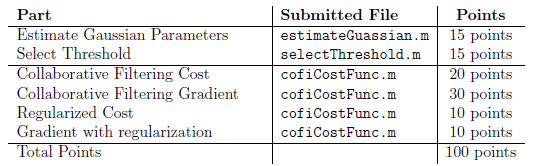

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.